### Preparation

clear
close all

support.fcn_download_img

lena.png already exists in ./data/
baboon.png already exists in ./data/
goldhill.png already exists in ./data/
barbara.png already exists in ./data/


### Parameter settings

- sgm: Standard deviation of noise $\sigma_w$ 

- nlevels: # of Tree levels

Let $R_M^P(\tau)$ be the redundancy of $\tau$-level tree-structured filter bank, then we have the relation 

    
$$R_M^P(\tau)=\left\{\begin{array}{ll} (P-1)\tau + 1, & M=1, \\ \frac{P-1}{M-1}-\frac{P-M}{(M-1)M^\tau}, & M\geq 2.\end{array}\right.$$


% Check initial state
checkInitialState = false

checkInitialState = logical
   0



% Number of iterations
nIters = 5;


% Decimation factor (Strides)
decFactor = [1 1] * 2 % [My Mx]

decFactor =      2     2



% Number of channels ( sum(nChannels) >= prod(decFactors) )
nChannels = [1 1] * 8% [Ps Pa] (Ps=Pa)

nChannels =      8     8


% Number of tree levels
nLevels = 4

nLevels = 4


% No DC-leakage
noDcLeakage = true

noDcLeakage = logical
   1



% Redundancy
P = sum(nChannels);
M = prod(decFactor);
redundancy = ...
    (prod(decFactor)==1)*((P-1)*nLevels+1) + ...
    (prod(decFactor)>1)*((P-1)/(M-1)-(P-M)/((M-1)*M^nLevels))

redundancy = 4.9844


% Polyphase Order
ppOrder = [1 1] *4

ppOrder =      4     4


% Parameter settins for LET
sigma =  10^-4

sigma = 1.0000e-04

isLET = true

isLET = logical
   1



% Parameter settings for soft-thresholding
lambda = 10^-1% -0.1

lambda = 0.1000


% Std of noise 
sgmuint8 = 20;
sgm = sgmuint8/255;

% Number of patchs per image
nSubImgs = 128;

% Patch size for training
szPatchTrn = [64 64 3]; % > [ (Ny+1)My (Nx+1)Mx ]

% Standard deviation of initial angles
stdInitAng = pi/6;

% Initial learning rate
initialLearnRate = 10^-2

initialLearnRate = 0.0100


% Learn rate factors (Set factor to 0 for frozen parameters)
factor4angles = 1; % NSOLT
factor4lambda = 1; % Soft-Th.
factor4sigma = 1; % LET
factor4a1 = 1; % LET
factor4a2 = 1; % LET
factor4b1 = 1; % LET
factor4b2 = 1; % LET
factor4gamma = 1; % Step-size

% L2 factors
l2factor4angles = 1; % NSOLT
l2factor4lambda = 1; % Soft-Th.
l2factor4sigma = 1; % LET
l2factor4gamma = 1; % Step-size

% Mini batch size
miniBatchSize = 32;

% Number of Epochs (1 Epoch = nSubImgs/miniBachSize iterlations)
maxEpochs = 32;

if checkInitialState
    maxEpochs = 1;
end

% Number of iterations
maxIters = nSubImgs/miniBatchSize * maxEpochs

maxIters = 128

## Read image

u = im2double(imread('./data/lena.png'));


## Observed image

- 
$$\mathbf{v}=\mathbf{Pu}+\mathbf{w}$$


- 
$$\mathbf{w}\sim\mathrm{Norm}\left(\mathbf{w}|\mathbf{\mu}_w=\mathbf{0},\sigma_w^2\mathbf{I}\right)$$


## Measurement Process

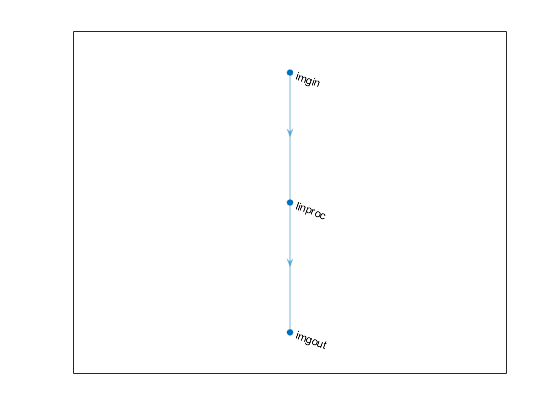

hsize = [9 9];
hsigma = 2;
downfactor = [2 2];
padopt = 'circ';
fwdproclayer = forwardMeasurement2dLayer(...
    'Name','linproc',...
    'Sigma',hsigma,...
    'PsfSize',hsize,...
    'PadOption',padopt,...
    'DecimationFactor',downfactor);
adjproclayer = fwdproclayer.createAdjointLayer();

% Simulation 
proclgraph = layerGraph();
proclgraph = proclgraph.addLayers([ ...
    imageInputLayer(size(u),'Name','imgin','Normalization','none'),...
    fwdproclayer,...
    regressionLayer('Name','imgout')]);
plot(proclgraph)

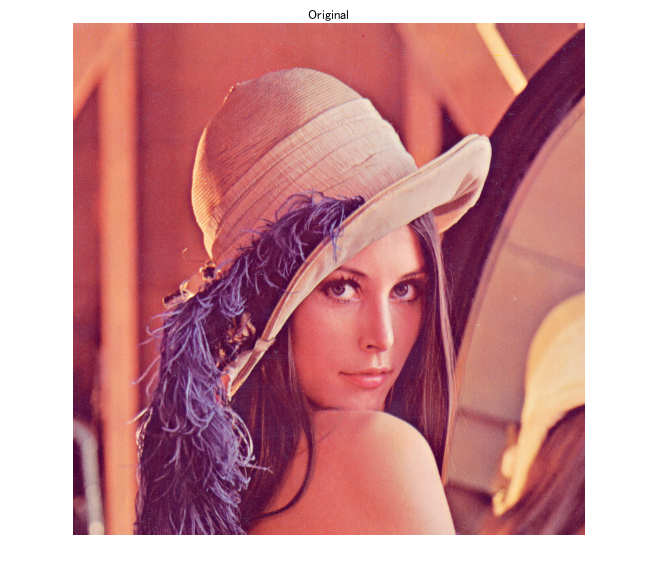

procnet = assembleNetwork(proclgraph);
v = imnoise(procnet.predict(u),'gaussian',0,sgm^2);

%
imshow(u)
title('Original')

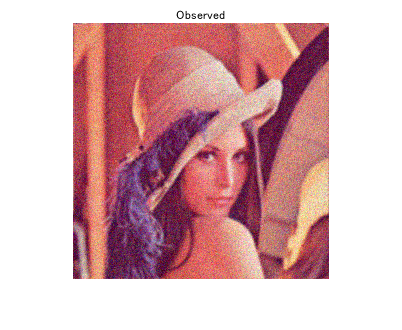

imshow(v)
title('Observed')

### Learned ISTA with Structured Convolutional Dictionary

#### References

- K. Gregor and Y. LeCun, "Learning fast approximations of sparse coding", *Proc. Int. Conf. Machine Learning*, pp. 399-406, 2010.

- V. Monga, Y. Li and Y. C. Eldar, "Algorithm Unrolling: Interpretable, Efficient Deep Learning for Signal and Image Processing," in IEEE Signal Processing Magazine, vol. 38, no. 2, pp. 18-44, March 2021, doi: 10.1109/MSP.2020.3016905.

- MATLAB SaivDr Package: [https://github.com/msiplab/SaivDr](https://github.com/msiplab/SaivDr)

- S. Muramatsu, K. Furuya and N. Yuki, "Multidimensional Nonseparable Oversampled Lapped Transforms: Theory and Design," in IEEE Transactions on Signal Processing, vol. 65, no. 5, pp. 1251-1264, 1 March1, 2017, doi: 10.1109/TSP.2016.2633240.

- S. Muramatsu, T. Kobayashi, M. Hiki and H. Kikuchi, "Boundary Operation of 2-D Nonseparable Linear-Phase Paraunitary Filter Banks," in IEEE Transactions on Image Processing, vol. 21, no. 4, pp. 2314-2318, April 2012, doi: 10.1109/TIP.2011.2181527.

- S. Muramatsu, M. Ishii and Z. Chen, "Efficient parameter optimization for example-based design of nonseparable oversampled lapped transform," 2016 IEEE International Conference on Image Processing (ICIP), Phoenix, AZ, 2016, pp. 3618-3622, doi: 10.1109/ICIP.2016.7533034.

- Furuya, K., Hara, S., Seino, K., & Muramatsu, S. (2016). Boundary operation of 2D non-separable oversampled lapped transforms. *APSIPA Transactions on Signal and Information Processing, 5*, E9. doi:10.1017/ATSIP.2016.3.

#### Problem setting:

    
$$\{\hat{\mathbf{\theta}},\{ \hat{\mathbf{s}}_n \}\}=\arg\min_{\{\mathbf{\theta},\{\mathbf{s}_n\}\}}\frac{1}{2S}\sum_{n=1}^{S}\left(\|\mathbf{v}_n-\mathbf{D}_{\mathbf{\theta}}\hat{\mathbf{s}}_n\|_2^2,\ +\lambda\|\mathbf{s}_n\|_1\right),$$$


where $\mathbf{D}_{\mathbf{\theta}}$ is a dictionary with the design parameter vector $\mathbf{\theta}}$.

#### ISTA

- Initialization: $\mathbf{s}^{(0)}$, $t\leftarrow 0$

- Proximal gradient descent: $\mathbf{s}^{(t+1)}\leftarrow \mathcal{T}_{\gamma \lambda}\left( \mathbf{s}^{(t)}-\gamma\nabla_\mathbf{s}f(\mathbf{s}^{(t)})\right)$

- If a stopping critera is satisfied then finish, otherwise $t\rightarrow t+1$ and go to Step 2.

where

- 
$$\nabla_\mathbf{s}f(\mathbf{s})=\mathbf{D}_{\mathbf{\theta}}^T\mathbf{P}^T(\mathbf{PD_{\mathbf{\theta}}\mathbf{s}-\mathbf{v})$$


- 
$$\mathcal{T}_{\gamma\lambda}(\mathbf{s})=\mathrm{sign}(\mathbf{s})\odot\max(\mathrm{abs}(\mathbf{s})-\gamma\lambda\mathbf{1},\mathbf{0})$$


- $\gamma<2/\beta$: Step size

- $\beta$: Lipschitz constant of $\nabla f$, where $\beta = (\sigma_{\mathrm{max}}(\mathbf{PD}))^2$

Step 2 of the ISTA can be written as follows

- 
$$\mathbf{s}^{(t+1)}\leftarrow \mathcal{T}_{\gamma g}\left(\mathbf{s}^{(t)}-\gamma\mathbf{D}_{\mathbf{\theta}}^T\mathbf{P}^T(\mathbf{PD}_{\mathbf{\theta}}\mathbf{s}^{(t)}-\mathbf{v})\right)$$


The above steps can equivalently be rewritten as a form of analysis, thresholding, and synthesis as follows.

#### Analysis-synthesis view of ISTA 

- Initialization: $\mathbf{s}^{(0)}$, $\mathbf{u}^{(0)}\leftarrow \mathbf{D}_{\mathbf{\theta}}\mathbf{s}^{(0)}$, $t\leftarrow 0$

- Residual: $\mathbf{r}^{(t)}\leftarrow \mathbf{P}^T(\mathbf{P}\mathbf{u}^{(t)}-\mathbf{v})$

- Analysis process: $\mathbf{y}^{(t)}\leftarrow \mathbf{D}_{\mathbf{\theta}}^T\mathbf{r}^{(t)}$

- Proximal gradient descent: $\mathbf{s}^{(t+1)}\leftarrow \mathcal{T}_{\gamma \lambda}\left(\mathbf{s}^{(t)}-\gamma\mathbf{y}^{(t)}\right)$

- Synthesis process: $\mathbf{u}^{(t+1)}\leftarrow \mathbf{D}_{\mathbf{\theta}}\mathbf{s}^{(t+1)}$

- If a stopping critera is satisfied then finish, otherwise $t\rightarrow t+1$ and go to Step 2.

The initialization part is set as

- 
$$\mathbf{s}^{(0)}\leftarrow \mathbf{D}^T_{\mathbf{\theta}}\mathbf{P}^T\mathbf{v}\Rightarrow\mathbf{u}^{(0)}\leftarrow \mathbf{P}^T\mathbf{v}$$


## Construction of layers

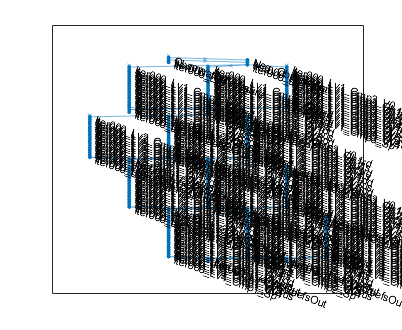

import saivdr.dcnn.*
nComponents = szPatchTrn(3);

% Parameter settings for step size
H = fftn(fwdproclayer.psf,2.^nextpow2([size(u,1) size(u,2)]));
beta = max(abs(H(:)).^2); % λmax(PP.')
gamma = 2./(beta+1e-2);

% Initialize
strIter = sprintf('Iter%03d_',0);
listalgraph = fcn_creatensoltlgraph2d(...
    'AppendInOutLayers',false,...
    'NumberOfComponents',nComponents,...
    'NumberOfChannels',nChannels,...
    'DecimationFactor',decFactor,...
    'PolyPhaseOrder',ppOrder,...
    'NumberOfLevels',nLevels,...
    'NumberOfVanishingMoments',noDcLeakage,...
    'Mode','Analyzer',...
    'Prefix',strIter);
imginputlayer0 = imageInputLayer(szPatchTrn./[decFactor 1],'Name','Observation','Normalization','none');
adjproclayer0 = adjproclayer;
adjproclayer0.Name = [strIter 'AdjMeasure'];
listalgraph = listalgraph.addLayers(...
    [imginputlayer0,adjproclayer0]);
%
strLv = sprintf('Lv%0d_',1);
listalgraph = listalgraph.connectLayers([strIter 'AdjMeasure'],[strIter strLv 'In']);

% Add intermediate result output
listalgraph = listalgraph.addLayers(nsoltIdentityLayer('Name',[strIter strLv 'Out']));
listalgraph = listalgraph.connectLayers([strIter 'AdjMeasure'],[strIter strLv 'Out']);

% Add Coefs. output
strLv = sprintf('Lv%0d_',nLevels);
listalgraph = listalgraph.addLayers(nsoltIdentityLayer('Name',[strIter strLv 'DcCoefsOut']));
listalgraph = listalgraph.connectLayers([strIter strLv 'DcOut'],[strIter strLv 'DcCoefsOut']);
for iLv = nLevels:-1:1
    strLv = sprintf('Lv%0d_',iLv);
    listalgraph = listalgraph.addLayers(nsoltIdentityLayer('Name',[strIter strLv 'AcCoefsOut']));
    listalgraph = listalgraph.connectLayers([strIter strLv 'AcOut'],[strIter strLv 'AcCoefsOut']);
end

% Add negative process
listalgraph = listalgraph.addLayers(scalingLayer('Name','Neg_Observation','Scale',-1));
listalgraph = listalgraph.connectLayers('Observation','Neg_Observation');

% Plot
plot(listalgraph)

import saivdr.dcnn.*
nComponents = szPatchTrn(3);
% Iteration
for iter = 1:nIters
    strIter = sprintf('Iter%03d_',iter);
    strIterPre = sprintf('Iter%03d_',iter-1);
    
    % Analysis-synthesis system
    nsoltlgraphi = fcn_creatensoltlgraph2d(...
        'AppendInOutLayers',false,...
        'NumberOfComponents',nComponents,...
        'NumberOfChannels',nChannels,...
        'DecimationFactor',decFactor,...
        'PolyPhaseOrder',ppOrder,...
        'NumberOfLevels',nLevels,...
        'NumberOfVanishingMoments',noDcLeakage,...
        'Prefix',strIter);
    for iLayer = 1:height(nsoltlgraphi.Layers)
        layer = nsoltlgraphi.Layers(iLayer);
        listalgraph = listalgraph.addLayers(layer);
    end
    for iConnection = 1:height(nsoltlgraphi.Connections)
        connection = nsoltlgraphi.Connections(iConnection,:);
        listalgraph = listalgraph.connectLayers(connection.Source{1},connection.Destination{1});
    end

    % Measurement processes
    fwdproclayeri = fwdproclayer;
    fwdproclayeri.Name = [strIter 'FwdMeasure'];
    adjproclayeri = adjproclayer;
    adjproclayeri.Name = [strIter 'AdjMeasure'];
    listalgraph = listalgraph.addLayers([fwdproclayeri,additionLayer(2,'Name',[strIter 'Residual']),adjproclayeri]);
    listalgraph = listalgraph.connectLayers([strIter 'AdjMeasure'],[strIter 'Lv1_In']);

    % Analyzer
    strLv = sprintf('Lv%0d_',1);
    listalgraph = listalgraph.replaceLayer([strIter strLv 'In'],...
        learnableScalingLayer('Name',[strIter strLv 'In'],'Scale',-gamma));

    % For DC
    strLv = sprintf('Lv%0d_',nLevels);
    listalgraph = listalgraph.disconnectLayers([strIter strLv 'DcOut'],[strIter strLv 'DcIn']);
    listalgraph = listalgraph.addLayers(nsoltIdentityLayer('Name',[strIter strLv 'DcCoefsIn']));
    listalgraph = listalgraph.addLayers(additionLayer(2,'Name',[strIter strLv 'DcCoefsResidual']));
    listalgraph = listalgraph.connectLayers([strIter strLv 'DcOut'],[strIter strLv 'DcCoefsResidual/in1']);
    listalgraph = listalgraph.connectLayers([strIter strLv 'DcCoefsIn'],[strIter strLv 'DcCoefsResidual/in2']);
    listalgraph = listalgraph.connectLayers([strIter strLv 'DcCoefsResidual'],[strIter strLv 'DcIn']);
    % For AC
    for iLv = nLevels:-1:1
        strLv = sprintf('Lv%0d_',iLv);
        listalgraph = listalgraph.disconnectLayers([strIter strLv 'AcOut'],[strIter strLv 'AcIn']);
        listalgraph = listalgraph.addLayers(nsoltIdentityLayer('Name',[strIter strLv 'AcCoefsIn']));
        listalgraph = listalgraph.addLayers(additionLayer(2,'Name',[strIter strLv 'AcCoefsResidual']));
        listalgraph = listalgraph.connectLayers([strIter strLv 'AcOut'],[strIter strLv 'AcCoefsResidual/in1']);
        listalgraph = listalgraph.connectLayers([strIter strLv 'AcCoefsIn'],[strIter strLv 'AcCoefsResidual/in2']);
    end

    % Synthesizer
    strLvPre = '';
    % For DC
    strLv = sprintf('Lv%0d_',nLevels);
    if iter < nIters
        listalgraph = listalgraph.addLayers(nsoltIdentityLayer('Name',[strIter strLv 'DcCoefsOut']));
        listalgraph = listalgraph.connectLayers([strIter strLv 'DcCoefsResidual'],[strIter strLv 'DcCoefsOut']);
    end
    % For AC
    for iLv = nLevels:-1:1
        strLv = sprintf('Lv%0d_',iLv);
        % For AC
        if isLET
            if iLv == nLevels
                listalgraph = listalgraph.addLayers(...
                    letLayer('Name',[strIter strLv 'AcTh'],'Sigma',sigma,... % Activation function for AC between Analyzer & Synthesizer
                    'IsInterScale',false,...
                    'NumberOfChannels',nComponents*(sum(nChannels)-1)));
                listalgraph = listalgraph.connectLayers([strIter strLv 'AcCoefsResidual'],[strIter strLv 'AcTh']);
            else
                listalgraph = listalgraph.addLayers(...
                    letLayer('Name',[strIter strLv 'AcTh'],'Sigma',sigma,... % Activation function for AC between Analyzer & Synthesizer
                    'IsInterScale',true,...
                    'NumberOfChannels',nComponents*(sum(nChannels)-1)));
                listalgraph = listalgraph.connectLayers([strIter strLvPre 'AcTh'],[strIter strLv 'AcTh/parent']);
                listalgraph = listalgraph.connectLayers([strIter strLv 'AcCoefsResidual'],[strIter strLv 'AcTh/child']);
            end
        else % Soft-thresholding
            listalgraph = listalgraph.addLayers(...
                sfthLayer('Name',[strIter strLv 'AcTh'],'Lambda',lambda,... % Activation function for AC between Analyzer & Synthesizer
                'NumberOfChannels',nComponents*(sum(nChannels)-1)));
            listalgraph = listalgraph.connectLayers([strIter strLv 'AcCoefsResidual'],[strIter strLv 'AcTh']);
        end
        listalgraph = listalgraph.connectLayers([strIter strLv 'AcTh'],[strIter strLv 'AcIn']);
        %
        if iter < nIters
            listalgraph = listalgraph.addLayers(nsoltIdentityLayer('Name',[strIter strLv 'AcCoefsOut']));
            listalgraph = listalgraph.connectLayers([strIter strLv 'AcTh'],[strIter strLv 'AcCoefsOut']);
        end
        %
        strLvPre = strLv;
    end
    
    % Connect iteration stages
    listalgraph = listalgraph.connectLayers([strIterPre 'Lv1_Out'],[strIter 'FwdMeasure']);
    listalgraph = listalgraph.connectLayers('Neg_Observation',[strIter 'Residual/in2']);
    %
    strLv = sprintf('Lv%0d_',nLevels);
    listalgraph = listalgraph.connectLayers([strIterPre strLv 'DcCoefsOut'],[strIter strLv 'DcCoefsIn']);
    for iLv = nLevels:-1:1
        strLv = sprintf('Lv%0d_',iLv);
        listalgraph = listalgraph.connectLayers([strIterPre strLv 'AcCoefsOut'],[strIter strLv 'AcCoefsIn']);
    end
end
%plot(listalgraph)

% Output
strIter = sprintf('Iter%03d_',nIters);
listalgraph = listalgraph.addLayers(regressionLayer('Name','Restoration'));
listalgraph = listalgraph.connectLayers([strIter 'Lv1_Out'],'Restoration');

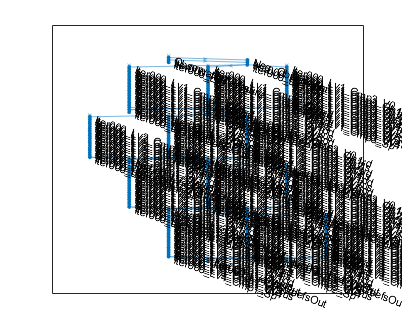

% Check
analyzeNetwork(listalgraph);

### Preparation of traning image

Randomly extracting patches from the image data store

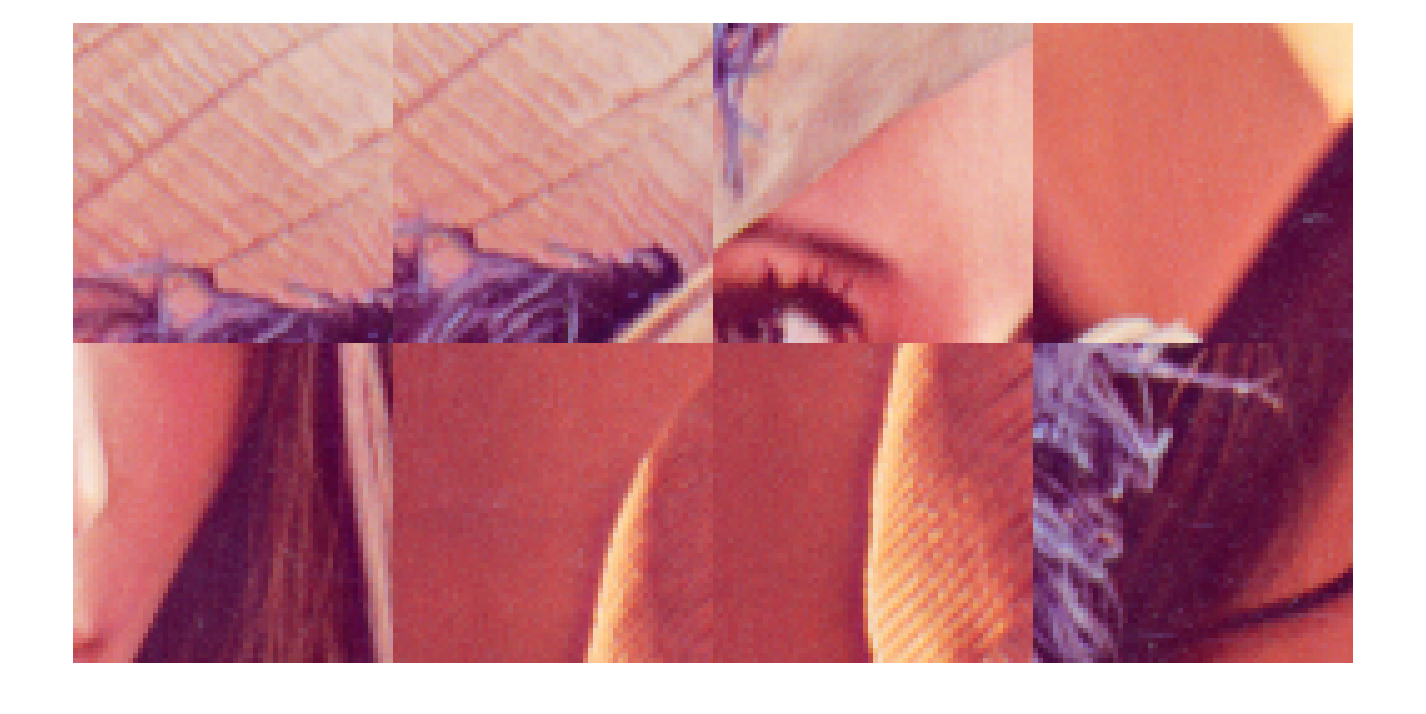

imds = imageDatastore("./data/lena.png","ReadFcn",@(x) im2single(imread(x)));
patchds = randomPatchExtractionDatastore(imds,imds,szPatchTrn,'PatchesPerImage',nSubImgs);
minibatch = preview(patchds);
responses = minibatch.ResponseImage;
montage(responses,'Size',[2 4]);

## Preperation of data set

proclgraph = layerGraph();
proclgraph = proclgraph.addLayers([ ...
    imageInputLayer(szPatchTrn./[decFactor 1],'Name','imgin','Normalization','none'),...
    fwdproclayer]);
procnet = dlnetwork(proclgraph);
obsds = transform(patchds, @(x) myobservation(x,procnet,sgm));

## Training options

opts = trainingOptions('sgdm', ... % Stochastic gradient descent w/ momentum
    ...'Momentum', 0.9000,...
    'InitialLearnRate',initialLearnRate,...
    ...'LearnRateScheduleSettings','none',...
    'L2Regularization',0.0,...1.0000e-04,... % Set zero since parameters are rotaion angles.
    ...'GradientThresholdMethod','l2norm',...
    ...'GradientThreshold',Inf,...
    'MaxEpochs',maxEpochs,...30,...
    'MiniBatchSize',miniBatchSize,...128,...
    'Verbose',1,...
    'VerboseFrequency',32,...50,...
    ...'ValidationData',[],...
    ...'ValidationFrequency',50,...
    ...'ValidationPatience',Inf,...
    ...'Shuffle','once',...
    ...'CheckpointPath','',...
    ...'ExecutionEnvironment','auto',...
    ...'WorkerLoad',[],...
    ...'OutputFcn',[],...
    'Plots','training-progress',...
    ...'SequenceLength','longest',...
    ...'SequencePaddingValue',0,...
    ...'SequencePaddingDirection','right',...
    ...'DispatchInBackground',0,...
    'ResetInputNormalization',0);...1

## Parameter initialization

listalgraph = listalgraph.removeLayers('Restoration');
listanet = dlnetwork(listalgraph);

% Initialize parameters
nLearnables = height(listanet.Learnables);
for iLearnable = 1:nLearnables
    if listanet.Learnables.Parameter(iLearnable)=="Angles"
        layerName = listanet.Learnables.Layer(iLearnable);
        listanet.Learnables.Value(iLearnable) = ...
            cellfun(@(x) x+stdInitAng*randn(size(x)), ...
            listanet.Learnables.Value(iLearnable),'UniformOutput',false);
    end
end

% Set learn rate factor & L2 factor
 for iLearnable = 1:nLearnables
     layerName = listanet.Learnables.Layer(iLearnable);
     parameterName = listanet.Learnables.Parameter(iLearnable);
     if parameterName == "Angles"
         listanet = listanet.setLearnRateFactor(layerName,"Angles",factor4angles);
         listanet = listanet.setL2Factor(layerName,"Angles",l2factor4angles);
     elseif parameterName == "Sigma"
         listanet = listanet.setLearnRateFactor(layerName,"Sigma",factor4sigma);
         listanet = listanet.setL2Factor(layerName,"Sigma",l2factor4sigma);
     elseif parameterName == "Lambda"
         listanet = listanet.setLearnRateFactor(layerName,"Lambda",factor4lambda);
         listanet = listanet.setL2Factor(layerName,"Lambda",l2factor4lambda);
     elseif ~isempty(regexp(layerName,'^Iter\d+_Lv\d+_In$','once')) && parameterName == "Scale" % gamma
         listanet = listanet.setLearnRateFactor(layerName,"Scale",factor4gamma);
         listanet = listanet.setL2Factor(layerName,"Scale",l2factor4gamma);
     elseif parameterName == "a1"
         listanet = listanet.setLearnRateFactor(layerName,"a1",factor4a1);
     elseif parameterName == "a2"
         listanet = listanet.setLearnRateFactor(layerName,"a2",factor4a2);
     elseif parameterName == "b1"
         listanet = listanet.setLearnRateFactor(layerName,"b1",factor4b1);
     elseif parameterName == "b2"
         listanet = listanet.setLearnRateFactor(layerName,"b2",factor4b2);
    end
end

### Learn rate factor

nParams = 0;
for iLearnable = 1:nLearnables
    layerName = listanet.Learnables.Layer(iLearnable);
    parameterName = listanet.Learnables.Parameter(iLearnable);
    learnRateFactor = listanet.getLearnRateFactor(layerName,parameterName);
    disp(parameterName + "@" + layerName + ": " + learnRateFactor);
    if learnRateFactor > 0
        value = listanet.Learnables.Value(iLearnable);
        nParams = nParams + numel(value{1});
    end
end

Angles@Iter000_Lv1_Cmp1_V0: 1
Angles@Iter000_Lv1_Cmp1_Vh1: 1
Angles@Iter000_Lv1_Cmp1_Vh2: 1
Angles@Iter000_Lv1_Cmp1_Vh3: 1
Angles@Iter000_Lv1_Cmp1_Vh4: 1
Angles@Iter000_Lv1_Cmp1_Vv1: 1
Angles@Iter000_Lv1_Cmp1_Vv2: 1
Angles@Iter000_Lv1_Cmp1_Vv3: 1
Angles@Iter000_Lv1_Cmp1_Vv4: 1
Angles@Iter000_Lv1_Cmp2_V0: 1
Angles@Iter000_Lv1_Cmp2_Vh1: 1
Angles@Iter000_Lv1_Cmp2_Vh2: 1
Angles@Iter000_Lv1_Cmp2_Vh3: 1
Angles@Iter000_Lv1_Cmp2_Vh4: 1
Angles@Iter000_Lv1_Cmp2_Vv1: 1
Angles@Iter000_Lv1_Cmp2_Vv2: 1
Angles@Iter000_Lv1_Cmp2_Vv3: 1
Angles@Iter000_Lv1_Cmp2_Vv4: 1
Angles@Iter000_Lv1_Cmp3_V0: 1
Angles@Iter000_Lv1_Cmp3_Vh1: 1
Angles@Iter000_Lv1_Cmp3_Vh2: 1
Angles@Iter000_Lv1_Cmp3_Vh3: 1
Angles@Iter000_Lv1_Cmp3_Vh4: 1
Angles@Iter000_Lv1_Cmp3_Vv1: 1
Angles@Iter000_Lv1_Cmp3_Vv2: 1
Angles@Iter000_Lv1_Cmp3_Vv3: 1
Angles@Iter000_Lv1_Cmp3_Vv4: 1
Angles@Iter000_Lv2_Cmp1_V0: 1
Angles@Iter000_Lv2_Cmp1_Vh1: 1
Angles@Iter000_Lv2_Cmp1_Vh2: 1
Angles@Iter000_Lv2_Cmp1_Vh3: 1
Angles@Iter000_Lv2_Cmp1_Vh4: 1
Angles@Iter0

disp("# of Parameters: = " + nParams)

# of Parameters: = 41465


NOTE: The above number excludes frozen parameters, whose learn rate factors are set to zero.

### L2 factor

for iLearnable = 1:nLearnables
    layerName = listanet.Learnables.Layer(iLearnable);
    parameterName = listanet.Learnables.Parameter(iLearnable);
    disp(parameterName + "@" + layerName + ": " + listanet.getL2Factor(layerName,parameterName))
end

Angles@Iter000_Lv1_Cmp1_V0: 1
Angles@Iter000_Lv1_Cmp1_Vh1: 1
Angles@Iter000_Lv1_Cmp1_Vh2: 1
Angles@Iter000_Lv1_Cmp1_Vh3: 1
Angles@Iter000_Lv1_Cmp1_Vh4: 1
Angles@Iter000_Lv1_Cmp1_Vv1: 1
Angles@Iter000_Lv1_Cmp1_Vv2: 1
Angles@Iter000_Lv1_Cmp1_Vv3: 1
Angles@Iter000_Lv1_Cmp1_Vv4: 1
Angles@Iter000_Lv1_Cmp2_V0: 1
Angles@Iter000_Lv1_Cmp2_Vh1: 1
Angles@Iter000_Lv1_Cmp2_Vh2: 1
Angles@Iter000_Lv1_Cmp2_Vh3: 1
Angles@Iter000_Lv1_Cmp2_Vh4: 1
Angles@Iter000_Lv1_Cmp2_Vv1: 1
Angles@Iter000_Lv1_Cmp2_Vv2: 1
Angles@Iter000_Lv1_Cmp2_Vv3: 1
Angles@Iter000_Lv1_Cmp2_Vv4: 1
Angles@Iter000_Lv1_Cmp3_V0: 1
Angles@Iter000_Lv1_Cmp3_Vh1: 1
Angles@Iter000_Lv1_Cmp3_Vh2: 1
Angles@Iter000_Lv1_Cmp3_Vh3: 1
Angles@Iter000_Lv1_Cmp3_Vh4: 1
Angles@Iter000_Lv1_Cmp3_Vv1: 1
Angles@Iter000_Lv1_Cmp3_Vv2: 1
Angles@Iter000_Lv1_Cmp3_Vv3: 1
Angles@Iter000_Lv1_Cmp3_Vv4: 1
Angles@Iter000_Lv2_Cmp1_V0: 1
Angles@Iter000_Lv2_Cmp1_Vh1: 1
Angles@Iter000_Lv2_Cmp1_Vh2: 1
Angles@Iter000_Lv2_Cmp1_Vh3: 1
Angles@Iter000_Lv2_Cmp1_Vh4: 1
Angles@Iter0

##  Training

単一の GPU で学習中。
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　エポック　　｜　　反復　　｜　　　　　経過時間　　　　　｜　　ミニバッチ　ＲＭＳＥ　　｜　　ミニバッチ損失　　｜　　基本学習率　　｜
｜　　　　　　　　｜　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　　　　　｜　　　　　　　　　　　｜　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　　　　　１　｜　　　　１　｜　　　　　００：０２：５１　｜　　　　　　　　１７．７２　｜　　　　　１５６．９　｜　　０．０１００　｜
｜　　　　　　８　｜　　　３２　｜　　　　　０１：３３：５４　｜　　　　　　　　　６．７９　｜　　　　　　２３．１　｜　　０．０１００　｜
｜　　　　　１６　｜　　　６４　｜　　　　　０３：０８：５９　｜　　　　　　　　　６．３６　｜　　　　　　２０．２　｜　　０．０１００　｜
｜　　　　　２４　｜　　　９６　｜　　　　　０４：４４：１５　｜　　　　　　　　　６．１３　｜　　　　　　１８．８　｜　　０．０１００　｜
｜　　　　　３２　｜　　１２８　｜　　　　　０６：２０：２５　｜　　　　　　　　　５．６５　｜　　　　　　１６．０　｜　　０．０１００　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜


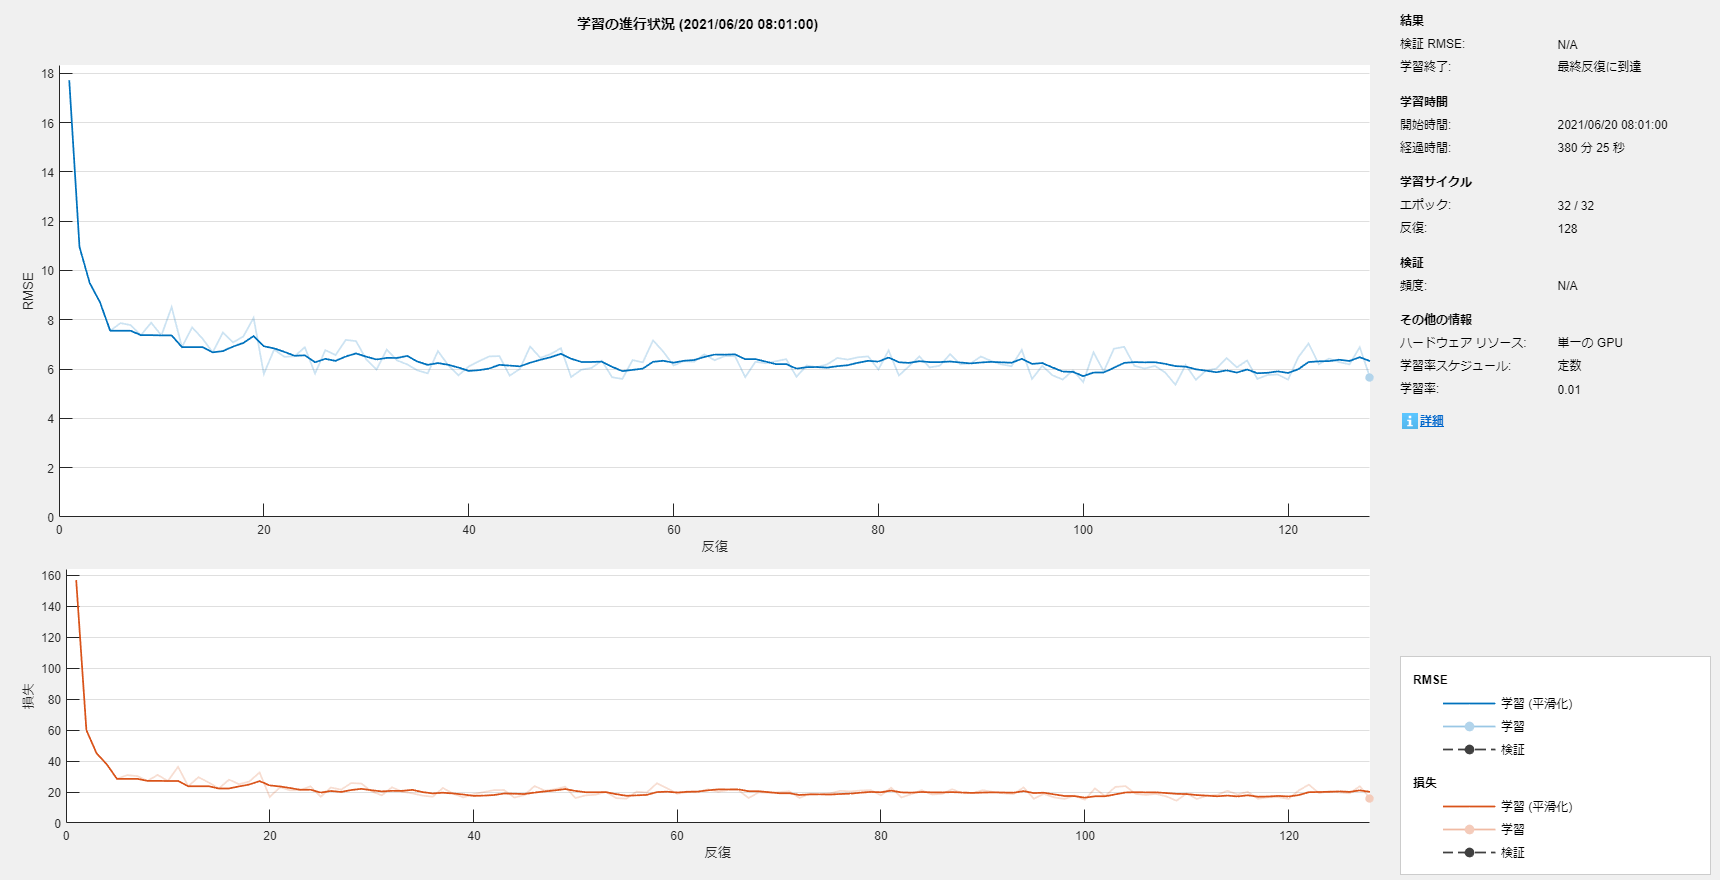

listalgraph = layerGraph(listanet); 
strIter = sprintf('Iter%03d_',nIters);
listalgraph = listalgraph.addLayers(regressionLayer('Name','Restoration'));
listalgraph = listalgraph.connectLayers([strIter 'Lv1_Out'],'Restoration');
trainednet = trainNetwork(obsds,listalgraph,opts);

save(sprintf('./data/nosoltlista_%s',datetime('now','Format','yyyyMMddhhmmssSSS')),'trainednet')

## Bicubic interpolation

For the sake of reference, the result with the bicubic interpolation is shown.

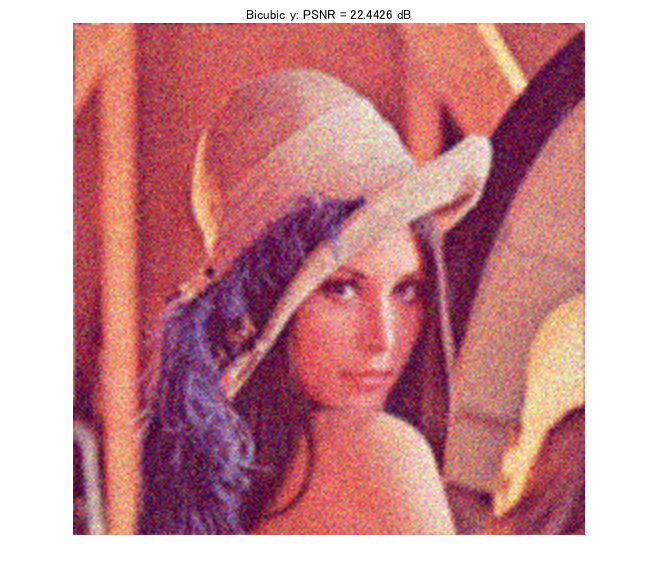

% Bicubic
y = imresize(v,2,'bicubic');
imshow(y)
title(['Bicubic y: PSNR = ' num2str(psnr(u,im2double(y))) ' dB']);

## Reconstruction by LISTA

Restoration by the trained network.

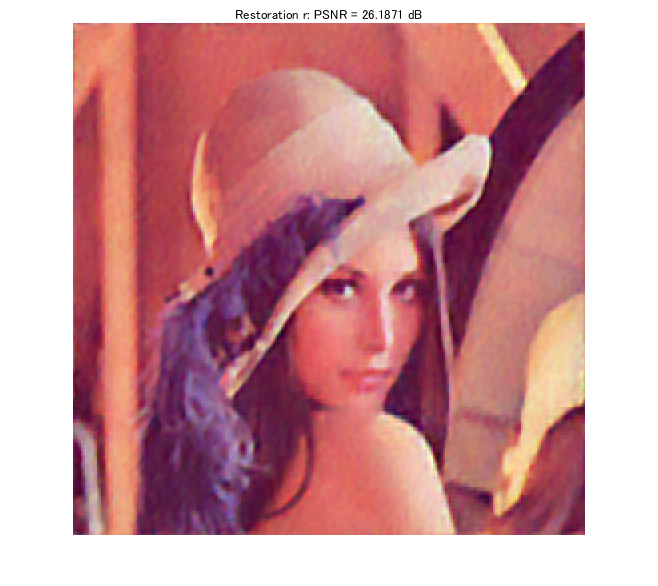

% Assemble LISTA
trainedlgraph = layerGraph(trainednet);
trainedlgraph = trainedlgraph.replaceLayer('Observation',...
    imageInputLayer(size(v),'Name','Image imput','Normalization','none'));
trainednet4predict = assembleNetwork(trainedlgraph);

% Process by LISTA
r = trainednet4predict.predict(v);
imshow(r)
title(['Restoration r: PSNR = ' num2str(psnr(u,im2double(r))) ' dB']);

## Learned parameters

trainedlgraph = layerGraph(trainednet);
trainedlgraph = trainedlgraph.removeLayers('Restoration');
trainednet = dlnetwork(trainedlgraph);

for iLearnable = 1:nLearnables
   learnables = trainednet.Learnables;
   disp(learnables.Parameter(iLearnable)+"@"+learnables.Layer(iLearnable)+":")
   disp(cell2mat(trainednet.Learnables.Value(iLearnable)))
end

Angles@Iter000_Lv1_Cmp1_V0:


  56×1 single dlarray

   -0.1426
    0.4121
   -0.1386
   -0.1175
    0.2513
    0.9019
   -0.2218
   -0.7735
   -0.1334
    0.4552
   -0.2673
    0.0183
    1.0634
    1.1827
   -0.5591
    0.8469
    0.9498
    0.7298
   -0.3722
   -0.7979
    0.1116
    0.9380
    0.4620
   -0.5419
    0.1159
    0.1302
    0.1267
   -0.1077
   -0.4775
   -0.3193
    0.5515
   -0.9163
    0.2072
   -1.0151
   -0.6954
   -0.1752
   -0.5320
    0.4552
   -0.5415
    0.7773
   -0.5706
    0.0283
    0.3539
    0.3126
   -0.1688
   -0.0484
    1.8997
   -0.1799
   -0.0353
    0.1931
    0.2106
   -0.2090
   -0.3209
    0.9078
   -0.1928
   -0.8908

  56×1 single dlarray



Angles@Iter000_Lv1_Cmp1_Vh1:


  28×1 single dlarray

    0.7949
   -0.5816
    0.8261
   -0.8583
   -0.1991
   -0.0287
    0.3139
    0.3955
   -0.1539
   -0.1314
    0.6180
   -0.1822
    0.5098
    0.4701
   -1.1124
    0.2049
   -0.4542
   -0.6454
   -0.6359
   -0.7484
    0.4002
    0.0482
   -0.6373
   -0.3064
    0.2928
    0.1444
    0.6671
    0.1874



Angles@Iter000_Lv1_Cmp1_Vh2:


  28×1 single dlarray

    0.1698
    0.7438
   -0.5363
    0.1337
   -0.0874
   -0.1552
    1.0353
   -0.4411
    0.1362
   -0.1506
   -0.1190
   -0.1669
   -0.0475
    0.1026
   -1.1179
    0.4728
    0.2110
    0.9049
    0.6432
    0.2497
    0.4257
    1.4562
   -0.2977
    0.7884
    0.2654
   -0.0834
    0.6630
   -0.3860



Angles@Iter000_Lv1_Cmp1_Vh3:


  28×1 single dlarray

    0.3401
    0.5441
   -0.5733
   -0.9036
    0.1738
   -0.3950
   -0.2153
   -1.3115
   -0.7329
   -0.7984
   -0.4767
   -0.7338
    0.2247
   -0.1660
   -0.4113
    0.1481
    0.4012
    0.6302
   -0.1878
    0.4797
    0.1488
   -0.9661
   -0.3645
   -0.0582
    0.8758
   -0.3928
   -0.3052
   -0.0515



Angles@Iter000_Lv1_Cmp1_Vh4:


  28×1 single dlarray

    0.3865
    0.6822
   -0.2559
   -0.0387
   -0.0302
   -0.2190
    0.1716
    0.6390
   -0.1475
    0.0179
   -0.0905
    0.0938
   -0.9244
   -1.0117
    0.3096
    0.5789
    0.1541
   -0.3497
   -0.4036
   -0.1289
    0.8510
    1.1617
    0.4078
    0.0373
   -0.5285
   -1.0292
    0.4367
   -0.6642



Angles@Iter000_Lv1_Cmp1_Vv1:


  28×1 single dlarray

   -0.3176
    0.3751
   -0.2248
   -0.1416
   -0.0206
   -0.3352
   -0.0039
   -0.1522
   -0.4233
    0.9209
    0.2378
   -0.7791
   -0.5095
    1.1076
   -0.5506
   -0.3600
    0.2717
    1.0263
    0.7816
   -0.0307
   -0.2985
   -0.2432
    0.4628
    0.5992
   -0.4286
   -0.1557
   -0.5081
    0.5755



Angles@Iter000_Lv1_Cmp1_Vv2:


  28×1 single dlarray

   -0.5078
    0.8524
   -0.3666
   -0.1375
   -0.0096
    0.8899
   -0.8360
   -0.1736
    0.1579
    0.6527
   -0.5007
   -0.3447
    0.9111
   -0.3045
    0.0499
   -1.0401
   -0.1784
   -0.0833
   -0.5888
   -0.3793
   -0.0429
   -0.4519
   -0.2085
    0.3376
    0.8825
   -0.4763
    0.6974
   -0.3218



Angles@Iter000_Lv1_Cmp1_Vv3:


  28×1 single dlarray

    0.5483
   -0.9210
    0.0166
   -0.0518
    0.3119
   -0.3205
   -0.9024
   -0.1870
    0.9268
   -0.2866
    0.4893
    0.0379
    0.3937
    1.3227
   -1.3781
   -0.2138
   -0.1390
    0.1765
    0.7720
    1.1291
    0.2317
    0.2183
    0.1266
   -0.0468
    0.1539
    0.1324
    1.0128
   -0.8188



Angles@Iter000_Lv1_Cmp1_Vv4:


  28×1 single dlarray

   -0.1110
   -0.7256
   -0.2169
    0.5802
    0.5235
   -0.1997
   -0.3574
    0.3653
    1.0483
   -0.1145
    0.0133
    0.1616
   -0.4696
    0.3194
   -0.3073
    0.7029
   -0.5537
   -0.4100
   -0.5253
    0.3619
    0.0449
    0.7170
   -0.1930
   -0.9607
   -0.3362
   -0.2333
    0.1780
   -0.5708



Angles@Iter000_Lv1_Cmp2_V0:


  56×1 single dlarray

   -0.6340
   -0.6064
   -2.2409
    0.8945
   -0.9470
   -0.6355
    0.0487
    0.5645
   -1.3319
   -0.1692
   -0.9500
   -0.0333
    0.8773
    0.3087
    0.2048
   -0.1723
   -1.2616
    0.5458
   -0.2050
   -0.1212
    0.4776
   -0.9939
   -0.8026
   -0.7136
   -0.9093
    0.2586
    0.0569
    0.0675
   -0.0020
    0.3058
   -0.8387
   -0.0565
    0.3506
    0.3639
   -0.6379
   -0.3873
   -0.1382
   -0.0495
   -0.2134
   -0.5891
    0.1347
   -0.2893
   -0.0573
    0.6251
    0.0311
   -0.3763
   -0.6577
   -0.0411
    0.2689
   -0.3915
    0.3220
   -0.8443
   -0.1374
   -0.1180
   -0.8986
   -0.2030

  56×1 single dlarray



Angles@Iter000_Lv1_Cmp2_Vh1:


  28×1 single dlarray

   -0.4926
    0.3603
   -0.0808
   -0.3571
    0.7399
   -0.3581
    0.5608
    0.2031
   -0.5368
    0.1720
    0.4942
    0.3530
   -0.1134
    1.2330
    0.0699
   -0.2472
   -0.2100
   -1.3676
    0.1915
    0.0527
   -0.7609
    0.0690
   -0.9867
    0.2806
   -0.0460
    0.0148
   -0.9758
    0.0248



Angles@Iter000_Lv1_Cmp2_Vh2:


  28×1 single dlarray

   -0.7692
    0.0837
   -0.1203
   -0.5319
   -0.5364
    0.7258
    0.1543
    0.6670
    0.0349
   -0.5884
    0.2664
    0.2875
    0.0589
   -0.6348
    0.1002
   -0.5007
    0.1460
    0.4803
   -0.8204
    0.2872
    0.7019
    0.8889
   -0.7227
    0.4533
    0.4660
   -0.0060
   -0.0243
    0.0360



Angles@Iter000_Lv1_Cmp2_Vh3:


  28×1 single dlarray

    0.7513
   -1.1911
    0.2315
   -0.2478
   -0.1304
   -0.0982
   -0.6144
    1.5198
   -0.2481
   -0.4614
   -0.3469
   -0.4267
   -0.3925
    0.4539
   -0.0387
   -1.3721
    0.6058
    0.6570
   -0.7123
   -0.0090
    0.3282
    1.1936
   -0.0739
   -0.2417
   -0.3119
    0.2223
   -0.7825
   -0.8950



Angles@Iter000_Lv1_Cmp2_Vh4:


  28×1 single dlarray

   -1.1689
    1.2529
   -0.0035
    0.2419
    0.6699
   -0.0638
    0.4517
    0.1739
   -0.4232
    0.5279
   -0.5679
   -0.6300
    0.3442
    0.7160
   -0.3954
   -0.3247
   -0.0790
    0.4352
    0.2477
   -0.2701
   -0.3032
   -0.4961
    0.0655
    0.5199
   -0.6060
   -0.0898
    0.8316
   -0.3129



Angles@Iter000_Lv1_Cmp2_Vv1:


  28×1 single dlarray

   -0.2702
    1.0386
   -0.1288
   -0.4417
    0.6367
    0.2261
    0.5887
   -0.8414
   -0.2063
    0.7772
    0.1477
   -0.2156
    0.5763
   -0.0396
    0.9398
   -0.5218
    1.0000
    0.8368
   -0.3402
   -0.1678
    0.6906
   -0.6395
    0.4570
   -0.1095
   -0.0468
    0.5356
   -0.4963
    0.0843



Angles@Iter000_Lv1_Cmp2_Vv2:


  28×1 single dlarray

    0.4705
   -0.0343
   -0.6058
   -0.3413
    1.0705
    0.9361
    1.4328
   -0.7219
    0.2738
   -0.7807
   -0.6179
   -0.5116
    0.1382
   -0.7993
    0.1716
    0.2532
    0.8803
   -0.0891
    0.3192
   -0.4591
   -0.5754
   -0.3349
    0.2886
   -0.2557
   -0.2508
   -0.6184
    0.1882
    0.7497



Angles@Iter000_Lv1_Cmp2_Vv3:


  28×1 single dlarray

    0.3852
   -0.9580
   -0.2584
    0.4869
    0.2946
   -0.2104
    0.1086
   -0.4722
   -0.5234
    0.2074
    0.1463
   -0.6338
    0.9395
   -0.4707
   -0.2577
   -0.0341
    0.0281
    0.0634
    0.3531
    0.2237
    0.8782
   -0.7288
   -0.0561
   -0.3881
   -0.1360
    1.3939
    0.0206
   -0.3965



Angles@Iter000_Lv1_Cmp2_Vv4:


  28×1 single dlarray

    0.4618
    0.0084
   -1.0948
    0.0917
    0.3227
   -0.6949
    0.6887
   -0.5862
    0.0498
   -0.6038
    0.7984
   -0.1193
    0.9558
   -0.6056
   -0.1411
    0.6067
   -0.3763
    0.1435
    0.0146
   -0.7447
    0.7797
   -0.1830
   -0.3308
    0.7993
   -0.0364
   -0.7121
   -0.2559
    0.0985



Angles@Iter000_Lv1_Cmp3_V0:


  56×1 single dlarray

   -0.1457
   -0.1423
   -0.1250
    0.3755
    0.3297
    0.1934
    0.8148
    1.4744
   -0.7085
   -0.1250
    0.5296
    0.0027
   -0.6705
    0.5486
    0.1720
   -1.0646
    0.2483
   -0.5694
   -0.7169
   -0.1043
   -0.1561
   -0.4654
    0.2232
   -0.0210
    0.4073
   -0.1405
    0.4466
    0.9980
   -0.0983
   -0.6401
    0.4102
   -0.5504
    0.6310
    1.1392
   -0.7670
    0.2550
    0.1765
    0.7750
   -0.0300
    0.2730
    0.2854
   -0.0274
    0.2111
    0.3163
   -0.0144
   -0.8005
   -0.0871
    0.5338
   -0.5063
   -0.3607
   -0.2762
   -0.3230
    0.3344
    0.2754
   -0.5766
   -0.4423

  56×1 single dlarray



Angles@Iter000_Lv1_Cmp3_Vh1:


  28×1 single dlarray

    0.2371
    0.0370
    0.7948
    0.3676
   -0.3498
    0.1660
    0.1122
    0.5687
   -0.3230
   -0.4102
   -0.2815
   -0.0103
    0.3585
   -0.0289
    0.5929
    0.6225
   -0.5395
    0.0590
   -0.0122
    0.2431
   -0.5055
   -0.0895
    1.1255
   -0.8646
   -0.1068
    0.1417
    0.6659
    0.0752



Angles@Iter000_Lv1_Cmp3_Vh2:


  28×1 single dlarray

   -0.5322
   -0.7223
   -0.2047
   -0.3001
    0.1143
    0.2114
   -0.4608
    0.5057
    0.0316
   -0.0715
   -0.3463
    0.1819
    0.9779
   -0.9230
    0.6448
   -0.2124
   -0.6445
   -0.0498
   -0.3027
    1.0046
    0.1459
   -0.1827
   -0.6059
    0.1622
   -0.4348
    0.1627
   -0.4982
    0.2661



Angles@Iter000_Lv1_Cmp3_Vh3:


  28×1 single dlarray

    0.0933
   -0.7711
   -0.1889
    0.3465
   -0.0508
   -0.3242
    0.2598
    0.5439
    1.2282
   -0.0368
    1.0391
    0.0436
   -0.1866
    0.8942
   -0.3804
    0.3044
   -0.1154
    0.0720
    0.5033
   -0.6775
   -0.2394
   -0.0412
   -0.1990
   -0.5469
   -0.0383
   -0.2830
   -0.7601
   -0.1996



Angles@Iter000_Lv1_Cmp3_Vh4:


  28×1 single dlarray

   -0.4712
   -0.3831
   -0.4157
   -0.0849
    0.2904
    0.3183
    0.4001
    0.1941
   -0.2284
   -0.9168
    0.1519
   -0.3138
    0.3158
   -0.4939
    0.1302
   -0.1357
   -0.6090
    0.1226
   -0.0414
   -1.2264
   -0.8668
   -0.2576
   -0.1401
    0.3463
   -0.0094
   -0.3068
   -0.0930
   -1.1631



Angles@Iter000_Lv1_Cmp3_Vv1:


  28×1 single dlarray

   -0.4530
    0.6402
    0.9199
   -0.6322
    1.1401
   -1.1487
    0.6873
    0.0496
   -0.0220
   -0.6946
   -0.1033
   -0.7731
   -0.3154
   -0.6719
    0.1264
    0.1761
    0.0697
    0.2448
    0.0686
   -0.6835
   -0.1721
    0.2311
   -0.0828
   -0.1980
   -0.0274
    0.8542
    0.4284
   -0.1743



Angles@Iter000_Lv1_Cmp3_Vv2:


  28×1 single dlarray

   -0.3508
    0.1686
    0.3042
    0.7738
   -0.2287
   -0.3248
    0.4658
    0.2244
    0.3607
    0.3050
    0.3443
    0.9598
    0.2425
   -0.9585
   -0.3074
    0.4623
    0.0622
    0.0347
   -0.6035
   -0.0913
   -0.2262
    0.7856
   -0.6883
   -0.5346
   -0.2770
    0.3905
   -0.8433
    1.1236



Angles@Iter000_Lv1_Cmp3_Vv3:


  28×1 single dlarray

   -0.1041
   -0.2053
    0.6177
    0.1448
   -0.9595
   -0.3956
    0.9542
    0.2076
   -1.3639
    0.5575
    0.6887
    0.4569
    0.5107
   -0.1707
    0.1664
   -0.4785
    0.0332
    0.6383
    0.6105
    0.3452
    0.0032
   -0.4875
   -0.0909
   -0.2325
   -0.5015
    0.5864
   -0.1081
    0.1127



Angles@Iter000_Lv1_Cmp3_Vv4:


  28×1 single dlarray

   -0.2133
    0.7388
    0.6538
   -0.7084
    0.9666
   -0.1836
    0.9715
   -0.0200
   -0.2308
    0.6770
    0.3405
   -0.6250
   -0.0087
   -0.4476
    0.3977
   -0.2868
    0.4717
    0.1875
   -0.0412
    0.6360
    0.0025
    0.2632
   -0.5299
   -0.7038
    1.4424
    1.0609
   -0.5274
    0.0535



Angles@Iter000_Lv2_Cmp1_V0:


  56×1 single dlarray

    0.3436
   -0.1129
   -0.0623
   -0.6278
    2.0320
    0.4266
   -0.3574
   -0.4317
    1.0269
    0.0981
    0.1261
    0.2081
    0.2743
    0.3509
   -0.3859
   -0.2115
   -0.6352
   -0.3595
    0.8801
   -0.3744
    0.0655
   -0.2193
    0.1315
    0.1773
    0.7909
   -0.4827
    0.2146
    0.4713
    0.9197
   -0.4166
    0.1813
   -0.0904
   -0.7705
   -0.1492
    0.3429
    0.6037
   -0.1876
    1.5293
    0.4280
   -0.9812
   -0.4517
   -0.1917
   -0.1835
   -0.6902
    0.3175
   -0.4263
   -0.5989
    0.1275
    0.5741
   -0.5206
    0.1705
   -0.1941
    0.1263
   -0.7077
    0.9326
    0.2593

  56×1 single dlarray



Angles@Iter000_Lv2_Cmp1_Vh1:


  28×1 single dlarray

    0.4473
    0.2117
   -1.0381
    0.4184
   -0.2765
   -1.0726
    0.0017
    0.5967
   -0.5244
    0.2313
   -0.1105
    0.3636
   -0.8071
    0.8859
    0.2290
   -0.5703
   -0.1916
   -0.0810
   -0.1335
    0.6523
    0.2180
    0.2918
   -0.2843
    0.2855
    0.4763
   -0.4687
    0.0118
    0.0860



Angles@Iter000_Lv2_Cmp1_Vh2:


  28×1 single dlarray

    0.2315
   -0.4928
   -0.3729
   -0.6399
    0.2370
   -0.1462
   -0.3485
   -0.4023
   -0.0453
   -0.2846
    0.0163
   -0.1381
    0.2827
   -0.4330
    0.2944
    0.7285
   -0.9268
    0.2565
   -0.1967
   -0.1302
    0.6378
   -0.2880
    1.2431
   -0.3655
   -0.0814
    0.1673
   -1.1011
   -0.3521



Angles@Iter000_Lv2_Cmp1_Vh3:


  28×1 single dlarray

   -0.1271
   -0.0143
   -0.0055
    0.0243
   -0.3805
    0.1101
   -0.4309
    0.2914
    0.0782
   -0.0556
    0.2702
   -0.5840
   -0.1675
   -0.1848
   -0.5360
   -0.7261
    0.5037
    0.0442
   -0.0963
   -0.4394
   -0.2495
    0.0448
    0.5308
    0.0848
   -0.4591
    0.7503
   -0.1217
   -0.5209



Angles@Iter000_Lv2_Cmp1_Vh4:


  28×1 single dlarray

    0.3705
    0.0484
   -0.3789
   -0.2377
    0.4418
   -0.2343
    0.1696
    0.4783
    0.6103
   -0.2010
    0.3563
    0.9843
    1.0408
    0.2962
    1.1590
   -0.5523
   -0.7503
   -0.6575
    0.1198
    0.5570
    0.0896
    0.2006
   -0.0046
   -0.0343
    0.4246
   -0.5989
    0.0953
    0.2437



Angles@Iter000_Lv2_Cmp1_Vv1:


  28×1 single dlarray

    0.7916
    0.4992
    0.0971
    0.4714
    0.0908
    0.2084
    0.5177
    0.2461
   -0.0762
   -0.5599
   -0.0112
    0.5350
    0.1558
    0.0104
    0.2339
   -0.3345
   -0.1199
    0.1853
   -0.9194
    0.9851
   -0.3121
    0.2278
   -0.1902
   -0.2013
   -0.0695
   -1.0884
   -0.2950
   -0.8192



Angles@Iter000_Lv2_Cmp1_Vv2:


  28×1 single dlarray

    0.3355
   -0.1512
    0.5874
   -0.1484
   -0.0034
   -0.2050
   -1.0976
    0.9531
    0.3628
    0.2239
   -0.5409
   -0.1068
   -0.2082
   -0.0261
    0.7019
   -0.1793
    0.2032
    0.6218
   -0.2193
   -0.5867
   -0.1618
   -0.3638
   -0.4273
    0.1054
   -0.5144
    0.1929
   -0.0037
   -0.3593



Angles@Iter000_Lv2_Cmp1_Vv3:


  28×1 single dlarray

    0.9737
    0.8302
   -0.5261
    0.1770
   -0.0592
    0.1355
    0.0679
    0.2666
   -0.3122
   -0.8250
   -0.0147
   -0.4111
    0.0121
    0.8858
   -0.4580
   -0.8093
   -0.8080
    0.4798
    0.2754
    0.2734
   -0.1886
   -0.0668
   -0.1039
    0.4357
   -0.5723
   -0.0554
   -0.8051
    0.8005



Angles@Iter000_Lv2_Cmp1_Vv4:


  28×1 single dlarray

   -0.6320
    0.6339
   -0.8117
   -0.2773
    0.2708
    0.0934
    0.1343
   -0.1327
    0.4171
    0.5877
   -1.1828
    0.8648
    0.6976
    0.0919
    0.1074
   -0.0480
    0.4585
    0.3327
   -0.1181
   -0.0858
   -0.7426
    0.2189
   -0.2428
    0.2342
    0.0122
   -0.4407
   -0.5472
    0.0442



Angles@Iter000_Lv2_Cmp2_V0:


  56×1 single dlarray

   -0.3562
    0.1512
    0.9932
   -0.0401
   -0.0058
    0.2174
   -0.4179
    0.5282
   -0.0796
    0.0961
    1.6783
   -0.2092
    0.0447
    0.3693
   -0.3274
   -0.2034
    0.2162
   -0.1740
   -0.5408
    0.2773
   -0.0916
   -0.2185
    0.2397
    0.6369
   -0.0369
   -0.2876
    0.1039
   -0.7693
    0.1743
   -0.7399
    0.1709
    0.2283
    0.1384
    0.2034
   -0.3618
    0.4322
    0.5267
   -0.1765
   -0.6151
   -0.6502
    0.7226
    0.3619
    0.2587
   -0.3510
    0.1823
   -0.0884
   -0.6775
    0.0739
   -0.1249
    0.2632
    0.4855
   -0.2024
   -0.1742
    0.4868
    1.1727
    0.0821

  56×1 single dlarray



Angles@Iter000_Lv2_Cmp2_Vh1:


  28×1 single dlarray

    0.0387
    0.7639
    0.4405
   -0.8261
    0.2916
    0.4994
   -0.2799
   -0.0934
    0.4971
    0.7755
   -0.7847
    0.0421
    0.3388
   -0.9201
   -1.1757
   -0.7097
   -0.1183
   -1.0157
   -0.3721
    0.5756
   -0.0700
   -0.7990
    0.8631
    0.2458
   -0.5650
   -0.3446
   -0.7004
    0.3893



Angles@Iter000_Lv2_Cmp2_Vh2:


  28×1 single dlarray

    0.8973
   -0.0837
    0.0546
   -0.4279
    0.9681
   -0.5757
   -0.1839
    0.3890
    0.9428
    0.9854
    0.7437
   -0.1542
    0.2540
    0.1214
   -0.7745
   -0.4239
   -0.0709
   -0.1460
    0.4380
    0.1290
    0.0311
   -0.8135
   -0.1183
   -0.1717
    0.2476
   -0.1557
    1.1343
    0.0925



Angles@Iter000_Lv2_Cmp2_Vh3:


  28×1 single dlarray

   -0.7901
    0.2207
   -0.2879
   -0.5176
   -0.6903
    0.0038
   -0.4769
   -0.4413
    0.2097
   -0.1018
   -0.6214
   -0.5353
   -0.7955
   -0.3039
   -0.0442
   -0.0696
    0.3100
    0.2483
   -0.5936
   -0.2560
   -0.0953
   -0.2694
    0.0842
   -0.2242
    0.2510
   -0.0889
    0.0124
    0.4643



Angles@Iter000_Lv2_Cmp2_Vh4:


  28×1 single dlarray

   -0.7118
    0.4972
   -0.7621
   -0.3995
   -0.5034
    0.2472
   -0.5532
    0.1988
    0.3948
    0.1666
    0.2383
    0.3368
    0.9225
    0.5418
    0.1394
    0.5241
    0.0423
   -0.3040
    0.2044
   -0.3859
    0.7567
   -0.3836
   -0.6030
   -0.1760
   -1.1302
    0.0267
   -0.5039
   -0.0383



Angles@Iter000_Lv2_Cmp2_Vv1:


  28×1 single dlarray

   -0.0505
   -1.0510
   -0.7996
    0.7440
    1.2329
    0.3974
    0.0184
   -0.0401
    0.1692
    0.8175
   -0.1606
    0.2677
   -0.5523
   -0.1915
   -0.0188
    0.1657
   -0.1224
    0.3007
   -0.1783
   -0.8268
   -0.2427
    0.7070
    0.4880
    0.0134
    0.0591
   -0.0509
    0.1141
    0.0903



Angles@Iter000_Lv2_Cmp2_Vv2:


  28×1 single dlarray

    0.5925
   -0.3840
   -0.2418
    0.9618
    0.4804
   -0.4519
    0.5615
   -0.3091
   -0.2014
   -0.2785
    0.9144
    0.2966
    0.5275
   -0.3725
   -0.3937
    0.1063
    1.0135
    0.4011
   -0.8781
    0.0888
    0.3150
   -0.1546
    0.8213
   -1.1445
   -0.5895
    1.1915
   -0.0622
   -0.3065



Angles@Iter000_Lv2_Cmp2_Vv3:


  28×1 single dlarray

   -0.2971
   -0.6115
   -0.0592
   -0.7927
   -0.2353
   -0.6964
   -0.2772
   -0.3133
   -0.0489
   -0.1875
   -0.0308
    0.8279
    0.3567
   -0.1894
    0.3232
    0.8242
    0.5598
   -0.5498
   -0.1119
   -1.1456
   -0.4188
   -0.8743
    0.1282
   -0.0425
    0.5788
   -0.2211
   -0.2507
    0.0852



Angles@Iter000_Lv2_Cmp2_Vv4:


  28×1 single dlarray

   -0.0776
   -0.2847
   -0.0819
   -0.8999
    0.4641
   -0.4482
   -0.1441
   -0.2616
   -1.5788
    0.6059
    1.1724
    0.2325
   -0.2227
   -1.2354
    0.2473
    1.2270
    0.1922
    0.5397
   -0.6144
    0.2373
    0.2348
   -0.0886
    0.1609
    0.1596
   -0.2334
   -0.5777
    0.6121
   -0.1021



Angles@Iter000_Lv2_Cmp3_V0:


  56×1 single dlarray

    0.4043
   -0.2305
    0.1885
    1.2508
    0.1012
    0.5445
    0.5320
   -0.6511
   -0.2539
   -0.1694
   -0.2935
   -0.2030
    0.4423
   -0.6775
    0.4506
   -0.0068
   -0.1557
    0.2749
   -0.3378
    0.6280
   -0.4405
    0.1725
   -0.5925
    0.1974
    0.5024
   -0.5148
   -0.3123
   -0.4104
   -1.3178
    0.5094
   -0.9219
   -0.0422
    0.1176
   -0.7335
    0.5499
    0.2239
   -0.2995
    0.8208
   -0.8859
   -0.5569
    0.4161
    0.9022
    0.0639
    0.3369
   -0.2509
   -0.6600
    0.2600
   -0.2075
   -0.1651
    0.4613
   -0.3787
   -0.1067
   -0.1137
   -0.2481
   -1.0715
   -0.2483

  56×1 single dlarray



Angles@Iter000_Lv2_Cmp3_Vh1:


  28×1 single dlarray

    0.8321
    0.7971
   -0.2739
    0.0390
   -0.1299
   -0.3746
    0.2612
    0.6054
    0.5842
    0.3138
   -0.2447
    0.2496
   -0.0208
    0.5406
   -0.1561
    0.1521
    0.0657
    0.1967
   -0.1614
   -0.2367
    0.5291
   -0.0087
    0.2024
    0.2132
   -0.0687
   -0.2215
   -0.3479
   -0.4320



Angles@Iter000_Lv2_Cmp3_Vh2:


  28×1 single dlarray

    0.5910
    0.1991
   -0.0171
   -0.2532
    0.0504
    0.2426
   -0.0636
    0.7414
    0.7861
    0.6551
   -0.3398
   -0.4541
   -0.7056
    0.8164
    0.1963
   -0.1888
   -0.5452
   -0.8096
    0.2416
    0.4871
   -0.6869
    0.1210
   -0.0686
    0.6381
    0.0390
    0.6666
   -1.1490
   -0.2652



Angles@Iter000_Lv2_Cmp3_Vh3:


  28×1 single dlarray

    0.2348
    0.8090
    0.2670
    0.3043
    0.2375
   -0.6815
    0.1969
   -0.8382
   -0.6940
   -0.8477
   -0.5374
   -0.9210
   -0.5928
   -0.8046
   -0.4238
    1.2377
    1.5427
   -0.2714
   -0.1748
   -0.0274
   -0.5568
    0.5876
    0.7224
   -0.4193
    0.4083
    0.5800
   -0.0594
   -0.6943



Angles@Iter000_Lv2_Cmp3_Vh4:


  28×1 single dlarray

    0.1054
    0.4635
    0.6796
   -0.7645
   -0.4533
    0.3285
    0.2544
    0.3227
   -0.7488
   -1.7118
   -0.0267
    0.3588
    0.5157
    0.3742
    0.3668
   -0.5139
    0.4281
    0.1597
   -0.4110
   -0.2700
    0.2410
    0.5297
   -0.2570
   -0.3722
   -0.0649
   -0.8016
    0.3180
    0.0215



Angles@Iter000_Lv2_Cmp3_Vv1:


  28×1 single dlarray

    0.0162
    1.2743
    0.0487
   -0.0217
    0.7032
    0.8652
   -0.5836
   -0.8062
    0.3137
    0.2313
    0.8611
   -0.0681
    0.1136
   -0.3193
   -0.9392
    0.0388
    0.6895
    0.0532
   -0.3234
   -1.2380
    0.3871
   -0.4241
    0.0782
   -0.3877
    0.9698
    0.3156
   -0.4089
    0.1446



Angles@Iter000_Lv2_Cmp3_Vv2:


  28×1 single dlarray

   -0.9272
    0.3839
    1.2374
   -0.6841
    0.0521
   -0.5065
   -0.1148
   -0.4801
    0.1549
    0.2553
   -0.2416
   -0.5225
   -0.7298
   -0.9047
   -0.1337
   -0.9076
    0.2547
   -0.3062
   -1.1206
   -1.0859
   -0.9389
    0.4425
   -0.3859
    0.4967
   -0.2252
   -0.0689
    0.5195
   -0.3334



Angles@Iter000_Lv2_Cmp3_Vv3:


  28×1 single dlarray

   -0.4209
    0.2594
    0.3198
   -1.3621
   -0.0766
   -0.1781
   -0.3819
    0.5348
   -0.4187
   -0.8516
   -0.3230
   -0.4891
   -0.2067
    0.5839
   -1.2229
    0.1457
    0.3661
    0.4986
   -0.7335
    1.2430
    0.2009
   -0.4808
    0.2019
    0.2748
   -0.2170
    0.6743
    1.1190
    0.3619



Angles@Iter000_Lv2_Cmp3_Vv4:


  28×1 single dlarray

   -0.7188
    0.4760
   -0.2785
   -0.8836
   -0.1710
   -0.8319
   -0.1239
    0.4362
    0.2580
    0.3625
    0.3357
   -0.2329
    0.5445
    1.1580
   -0.6745
    0.0875
   -0.8939
    0.7435
    0.1514
   -0.5891
   -0.3982
    0.3904
   -0.1001
    0.0936
    1.1219
    0.2734
    0.0949
   -0.6037



Angles@Iter000_Lv3_Cmp1_V0:


  56×1 single dlarray

   -0.4610
   -0.3062
    0.2663
    0.2374
   -0.3573
   -0.9332
   -0.6982
    1.4107
   -0.1441
   -0.1067
    0.2189
   -0.2441
    0.3125
   -0.0942
    0.3034
   -0.3163
   -0.4351
    0.1477
    0.2429
    1.1199
   -0.2377
   -0.6257
   -0.6291
    0.9439
   -0.2589
   -0.3849
   -0.4031
   -0.6456
   -0.0547
    0.0333
    0.4139
    0.4178
    0.0093
    0.9644
    0.4932
   -0.5184
   -0.8822
   -0.2046
   -0.1133
   -0.0913
    0.8657
   -1.1769
   -0.2540
   -0.4161
   -0.1669
    1.3112
    0.1798
    0.0089
   -0.7301
   -0.2221
    0.2278
    0.4887
    0.1609
   -0.1659
   -0.0110
    1.4587

  56×1 single dlarray



Angles@Iter000_Lv3_Cmp1_Vh1:


  28×1 single dlarray

    0.0035
   -0.0908
   -0.3215
   -0.0585
    0.2732
    0.4982
    0.2980
    0.2838
    0.1344
    0.4636
   -0.3536
   -0.3360
   -0.1844
    0.3294
    0.1330
   -0.0367
   -0.0293
   -0.1588
   -0.4764
    0.0009
    0.7726
   -1.3787
   -0.0569
    0.3473
    0.3457
   -1.1021
    0.0376
   -0.1908



Angles@Iter000_Lv3_Cmp1_Vh2:


  28×1 single dlarray

   -0.9505
    0.1227
    0.6571
    0.3927
   -0.4149
   -0.0213
   -0.3217
    0.5478
   -0.3745
    0.2069
    0.1889
    0.2341
   -0.1367
    0.3134
   -0.8651
   -0.2226
   -0.3977
    1.0428
   -0.5585
   -0.7394
    0.3573
    0.2128
   -0.4442
    0.2149
   -0.3072
    0.5042
   -0.5339
    0.5859



Angles@Iter000_Lv3_Cmp1_Vh3:


  28×1 single dlarray

   -0.0538
   -0.1383
    1.2640
    0.1623
   -0.3152
    0.0697
   -0.0437
   -0.7220
    0.0099
   -0.2475
    0.3859
    0.2726
   -0.6204
   -0.7296
   -0.3031
    0.2250
   -0.2230
   -0.1659
   -1.0166
   -0.3755
    1.1485
    0.1584
   -0.2108
    0.2651
    0.4132
    0.3018
   -0.0297
    0.0866



Angles@Iter000_Lv3_Cmp1_Vh4:


  28×1 single dlarray

   -0.3327
   -0.1379
   -0.5322
   -0.2353
   -0.9768
    0.4597
   -0.6539
   -0.0699
    0.3621
   -0.2011
   -0.6140
   -0.3328
   -0.4216
    0.0955
    0.8783
   -0.2014
    0.5654
   -0.2116
   -0.5960
    0.0311
    0.4277
   -0.2672
    0.4224
   -0.0837
   -0.1123
    0.4995
   -0.2083
   -0.3669



Angles@Iter000_Lv3_Cmp1_Vv1:


  28×1 single dlarray

    0.4463
   -0.5861
    0.0680
    0.2187
   -0.0517
    0.1246
    0.3400
   -0.9899
   -0.4771
    0.0836
   -0.0225
   -0.2833
   -0.1535
    0.1289
    0.0499
   -0.0849
    0.3273
   -0.6453
   -0.0767
   -0.5920
    0.0237
   -0.0147
    0.3484
    0.0763
    0.3801
    0.0905
    0.8510
   -0.2402



Angles@Iter000_Lv3_Cmp1_Vv2:


  28×1 single dlarray

   -0.6416
   -0.6262
   -0.2170
    1.0424
    1.1302
   -0.8477
   -1.0135
    0.4414
   -0.3945
    0.4072
    0.1872
   -0.3432
    1.2991
   -0.0947
   -0.4268
   -0.4428
    0.6065
   -0.1567
    0.0150
    0.9522
    0.3908
    0.2919
    0.9729
    0.0516
    0.4414
   -0.5080
    0.3149
    0.1346



Angles@Iter000_Lv3_Cmp1_Vv3:


  28×1 single dlarray

    1.0284
   -0.3412
    0.7983
    0.9242
   -0.5000
    0.4586
   -0.7863
    0.3784
    0.2812
    0.4205
    0.1802
    0.4253
    0.6278
   -0.3071
    0.8189
    0.1337
    0.6966
   -0.0798
    0.6569
    0.2998
   -0.0148
   -0.0917
    0.1314
    0.1011
   -0.0987
    0.6855
    0.0255
   -0.1088



Angles@Iter000_Lv3_Cmp1_Vv4:


  28×1 single dlarray

    0.5714
    0.7041
   -1.1716
   -0.8289
    0.1992
    0.3951
    0.2850
   -0.1775
   -0.0790
    0.2064
    0.1787
   -0.8093
    0.3099
   -0.7419
   -0.2046
   -0.2610
    0.0615
    0.0606
   -0.0554
    0.2930
    0.3847
    0.1331
   -0.3167
    0.0679
   -0.6270
    0.7964
    0.0229
   -0.0360



Angles@Iter000_Lv3_Cmp2_V0:


  56×1 single dlarray

    0.3109
   -0.2888
    0.0265
    0.6313
    0.0043
    0.7870
   -0.9045
   -0.0801
    0.5785
   -1.5801
   -0.4845
   -0.3341
    0.2933
    0.0994
    0.4633
    0.0280
    0.7744
   -1.2537
    0.4897
    0.4923
   -1.1044
   -0.6326
   -0.5228
    0.3273
   -0.6792
    0.4359
    0.4110
   -0.6710
   -1.2885
    0.2944
   -0.3139
    0.6546
    0.9098
   -0.6152
    0.4236
    0.3467
   -0.2516
    0.3605
   -1.0876
   -0.1052
   -0.4807
   -0.5565
   -0.9412
   -0.1820
    1.5362
    0.7105
   -0.1448
   -0.4011
    0.0715
   -0.7305
    0.2202
   -0.1968
    1.1196
   -0.1699
    0.2988
   -0.6040

  56×1 single dlarray



Angles@Iter000_Lv3_Cmp2_Vh1:


  28×1 single dlarray

    0.8060
    0.9020
   -0.5868
   -0.1644
    1.0718
   -0.5172
    0.1183
    1.1405
   -0.2060
   -0.0530
    0.0268
    0.2412
    0.0052
    1.2565
   -0.1649
   -0.6952
    0.1346
    0.3611
    0.0487
   -1.3453
   -0.2274
   -0.3789
   -0.2455
    0.1992
   -0.0744
    0.4569
   -0.0881
   -0.1018



Angles@Iter000_Lv3_Cmp2_Vh2:


  28×1 single dlarray

    0.1619
   -0.2909
    0.6760
    0.2639
   -1.0114
    0.3643
   -0.3371
   -0.4891
   -0.8809
    0.3505
   -0.2442
   -0.5257
   -0.7442
    0.1048
    0.2280
    0.2848
   -0.6427
    0.3880
   -0.4129
    0.2495
   -0.3609
    0.3685
   -0.1362
   -0.5812
   -1.5624
   -0.4116
    0.1495
   -0.6491



Angles@Iter000_Lv3_Cmp2_Vh3:


  28×1 single dlarray

    0.3128
   -0.4498
    0.5526
   -0.0586
    0.1176
    0.1258
   -0.7222
   -0.4174
    0.8185
   -0.2337
    0.4768
    0.0633
   -0.1208
   -0.3470
    0.1382
   -0.1369
    0.3449
    0.8047
   -0.6170
    0.1709
    0.3557
   -0.3232
    0.1723
    0.3149
   -0.1979
    0.3298
   -0.5786
   -0.0430



Angles@Iter000_Lv3_Cmp2_Vh4:


  28×1 single dlarray

   -1.1596
    0.5734
   -0.4343
   -0.6728
    0.0445
   -0.0616
   -0.3796
   -0.5263
    0.1123
   -0.4318
    0.2118
   -0.0344
   -0.0630
    0.4071
    0.6607
    0.2019
   -0.6668
   -0.1928
    0.1322
    1.1540
    0.3202
   -0.7191
   -0.6369
   -0.2689
   -0.7095
   -0.2180
    0.8507
   -0.0168



Angles@Iter000_Lv3_Cmp2_Vv1:


  28×1 single dlarray

    0.1214
    0.7681
   -0.6829
   -1.3578
    0.6360
   -0.2071
    0.0755
    0.6014
    0.1611
    0.8143
   -0.8129
   -0.1455
    0.5750
   -0.0398
    0.1264
   -0.9114
   -0.0089
   -0.2248
   -0.6644
   -0.3774
    0.5915
    0.0437
   -0.3368
    0.6579
    0.0018
    0.6083
   -0.3077
   -0.7590



Angles@Iter000_Lv3_Cmp2_Vv2:


  28×1 single dlarray

   -0.7164
   -0.5882
    1.2226
    0.1131
   -0.2773
    0.1202
    0.1946
    0.2205
    1.2650
   -0.5796
   -0.2217
   -0.1166
    0.1572
    1.4168
    0.9282
   -1.3203
   -0.2288
   -0.0674
   -0.0168
    0.3420
   -0.2598
    0.5065
    0.6054
    0.7142
    0.1479
   -0.3385
   -0.5034
   -0.3580



Angles@Iter000_Lv3_Cmp2_Vv3:


  28×1 single dlarray

    0.3130
   -0.3190
   -0.0124
    0.0028
   -0.9680
    0.7701
   -0.1339
   -0.4872
    0.2396
    0.0185
    0.4958
    0.3582
   -0.3337
   -0.3674
   -0.8022
    0.0639
   -0.6028
   -0.7840
    0.5872
    0.3450
   -1.2153
    0.4424
   -0.3010
   -0.5767
    0.9296
   -0.4031
    0.6056
   -0.7295



Angles@Iter000_Lv3_Cmp2_Vv4:


  28×1 single dlarray

   -0.6607
   -0.0993
   -0.0614
    0.5764
   -0.5597
    0.3877
   -0.2256
    0.0891
    0.1712
   -0.4261
   -0.2556
    0.2915
   -0.1385
   -0.8877
    0.5130
   -0.7495
    0.5090
    0.2667
   -0.4240
    0.1422
   -0.2549
   -0.4078
   -0.5928
   -1.4995
   -0.2892
   -0.1564
   -0.5442
   -0.2763



Angles@Iter000_Lv3_Cmp3_V0:


  56×1 single dlarray

    0.1752
    0.1840
   -0.3740
    0.2385
   -0.0153
    0.3503
    0.1691
    0.2834
   -0.6384
    0.3320
    0.5466
   -0.0974
    0.9699
   -0.1687
   -0.8547
    0.0890
   -0.6752
   -0.3774
    0.8614
    0.2682
    0.3166
    0.0143
    0.2647
    0.1644
    0.0729
   -0.2117
    1.4704
   -0.2570
    0.0288
    0.0923
    0.3580
   -0.7194
   -0.1593
   -0.5066
    0.7880
   -0.0735
    0.2513
   -0.0672
    0.4757
    0.4902
   -0.2580
    0.7509
    0.4403
    0.2816
   -0.3798
    0.0990
    0.6498
   -0.1234
   -1.0353
   -0.6699
    0.5138
   -0.3083
   -0.3973
    0.5099
   -0.1292
    0.5616

  56×1 single dlarray



Angles@Iter000_Lv3_Cmp3_Vh1:


  28×1 single dlarray

   -0.4958
    0.2860
   -0.5449
   -0.8187
   -0.4923
   -0.1793
   -0.3670
    0.7901
   -0.3924
    0.2998
   -0.1097
   -0.6140
    0.7082
    0.0890
   -0.1476
    0.1953
   -0.0381
   -0.3716
    0.6883
   -0.3053
    0.1235
   -0.7973
    0.9554
    0.6247
   -0.1510
    0.0551
    0.0408
    0.5025



Angles@Iter000_Lv3_Cmp3_Vh2:


  28×1 single dlarray

    0.2128
   -0.3596
    0.0211
    0.4213
   -0.2672
    0.2667
    0.6066
    0.5902
    0.2627
    0.2632
    0.3572
    0.0522
   -0.2580
    1.0562
   -0.0507
   -0.4731
   -0.2398
    0.0629
   -0.4174
   -0.0040
    0.3538
   -0.4973
    0.2910
    0.0222
    0.1798
   -0.2506
   -0.3236
    0.1335



Angles@Iter000_Lv3_Cmp3_Vh3:


  28×1 single dlarray

    0.4153
   -0.6871
    0.2553
   -0.2996
   -0.3547
   -0.8302
    0.5942
    0.3761
   -0.5587
   -0.4375
   -0.0487
   -0.1448
   -0.1439
    0.5339
    0.0542
    0.3035
   -0.5576
   -0.2091
    0.6098
    0.4304
    0.9220
   -0.6943
   -0.3800
    0.9760
    0.2389
   -0.3327
    0.4736
   -0.4621



Angles@Iter000_Lv3_Cmp3_Vh4:


  28×1 single dlarray

   -0.3180
    0.6768
    0.6056
    0.2350
    0.1239
   -0.1613
   -0.4601
    0.1401
    0.3458
   -0.4741
   -0.5104
   -0.5854
   -0.1517
    0.2937
   -0.0224
   -0.2296
    0.5122
   -0.5075
   -0.6594
    0.1333
    0.2697
    0.6943
   -0.4560
    0.0345
    0.3189
   -1.0288
    0.4789
   -0.1393



Angles@Iter000_Lv3_Cmp3_Vv1:


  28×1 single dlarray

   -0.0046
   -0.6214
    0.4616
    0.7415
    0.3267
   -0.1370
    0.3356
   -0.0836
    0.2853
    0.0939
   -0.0168
    0.3454
   -0.2736
    0.7183
   -0.4882
   -1.3474
   -0.1086
    0.3768
   -0.6286
    0.9040
   -0.1678
    0.1175
   -0.1783
   -0.9503
   -0.3512
    0.9881
    0.0531
   -0.2554



Angles@Iter000_Lv3_Cmp3_Vv2:


  28×1 single dlarray

    0.4915
   -0.8133
   -0.5116
    1.5145
   -0.3725
    0.5296
    0.5820
    0.3090
    1.6889
    0.5712
    0.4560
    0.1374
   -0.5589
    0.5976
   -0.0331
   -0.4560
   -0.0240
   -0.2574
   -0.8201
    0.1303
    0.9724
    0.1786
    0.0364
   -0.5691
    0.4754
    0.0309
   -0.7539
    0.5542



Angles@Iter000_Lv3_Cmp3_Vv3:


  28×1 single dlarray

   -0.3110
    0.0314
   -0.0319
    1.1273
    0.4298
    1.1156
   -0.2178
    0.0523
   -1.1830
   -0.1149
   -0.1905
   -0.3235
   -0.3407
    0.3061
    0.1101
   -0.5504
   -0.1882
    0.2933
   -0.5814
   -0.3256
    0.2380
    0.2703
    0.1355
   -0.7205
   -0.5931
   -0.2395
    0.0160
   -0.7316



Angles@Iter000_Lv3_Cmp3_Vv4:


  28×1 single dlarray

    0.6878
   -0.2714
    0.4155
   -0.7624
   -0.1498
   -0.7452
   -0.1606
   -0.0950
    0.0299
    0.3528
   -0.1919
    0.1644
   -0.3685
   -0.4486
    0.4112
    0.6873
    0.1438
   -0.5975
   -0.0637
    0.0439
    0.5079
    0.5943
   -0.6554
    0.0073
    0.3537
   -0.2062
    0.5418
   -0.4164



Angles@Iter000_Lv4_Cmp1_V0:


  56×1 single dlarray

    0.4264
    0.7745
   -0.5385
    0.4371
   -0.8808
    0.4742
   -0.0128
   -0.4329
    0.4115
   -0.5120
   -0.3457
    0.9157
    0.5557
   -0.2257
    0.6042
   -0.2575
   -0.4724
    0.0281
    0.0256
    0.3174
   -0.5289
   -0.6270
    0.2839
    0.6985
    0.2343
   -0.1612
    0.5708
   -0.8835
    0.2415
   -0.1985
   -0.8868
    0.0311
   -0.7585
    0.5993
   -0.3047
    0.0091
   -0.2063
    0.7529
    0.4898
   -0.3350
    0.4916
   -1.1869
   -0.5830
    0.4325
    0.6154
   -1.1032
   -0.0181
    0.0541
    0.4081
   -0.6290
   -0.0210
    0.0490
   -0.0920
    0.1135
    0.5663
   -0.1374

  56×1 single dlarray



Angles@Iter000_Lv4_Cmp1_Vh1:


  28×1 single dlarray

    0.9483
    0.0509
    0.2320
    0.5669
   -0.0983
    1.1718
    0.2707
   -0.1658
    0.2802
   -1.6491
    0.1308
    0.4568
    0.5709
   -0.4212
   -0.8423
   -0.0809
    0.0150
    0.4881
    0.3284
   -0.6347
   -0.3853
    0.2307
    0.1803
    0.5126
    0.3614
   -0.0548
    0.0487
    0.3894



Angles@Iter000_Lv4_Cmp1_Vh2:


  28×1 single dlarray

    0.0183
   -0.1927
   -0.7666
    0.8761
   -0.1039
    0.2482
    0.1154
    1.5724
   -0.4693
    0.6978
   -0.0890
    0.5603
    0.0757
   -0.0841
   -0.0129
   -0.3709
   -1.0082
   -0.3465
   -1.0620
    0.5385
   -0.1675
   -0.4058
    0.0726
   -0.5984
    0.1959
    0.2901
   -0.7693
   -0.5177



Angles@Iter000_Lv4_Cmp1_Vh3:


  28×1 single dlarray

    0.3009
   -1.0110
    0.8356
    0.4743
   -0.8893
   -0.5278
    0.7754
   -0.3298
    0.9453
    0.5754
   -0.4892
    0.4947
    0.1193
   -0.9103
    0.4484
    0.0054
    0.9653
    0.0243
    1.3457
   -0.2361
    0.2788
   -0.0124
    0.6776
   -0.0154
   -0.1027
    0.9385
    0.5598
    0.2518



Angles@Iter000_Lv4_Cmp1_Vh4:


  28×1 single dlarray

    1.2477
    0.1586
    0.3566
    0.1870
    0.9833
    0.1626
    0.1686
   -0.0982
    0.2859
    0.9151
   -0.3965
   -0.8773
    0.5299
    0.7260
   -0.0023
    0.4632
    0.4054
   -0.5136
    0.3448
   -0.3822
    0.2596
   -0.4515
    1.2111
    0.4154
    0.0575
    0.0070
   -0.4805
    0.6279



Angles@Iter000_Lv4_Cmp1_Vv1:


  28×1 single dlarray

    0.6237
    0.1372
   -0.7803
    0.1726
   -0.1250
    0.2262
   -0.5387
    0.7336
    0.4969
    0.3656
   -0.7924
   -0.1087
    0.5909
   -0.0876
   -0.8329
    0.2985
    0.2209
    0.3500
    0.2861
   -0.1310
    0.5249
   -0.8291
   -0.7450
   -0.2220
    0.1042
    0.6445
    0.6208
   -1.2501



Angles@Iter000_Lv4_Cmp1_Vv2:


  28×1 single dlarray

   -0.3710
   -0.2803
    0.4475
   -0.4999
   -0.4708
    0.1400
    0.4773
   -1.1234
    0.2672
   -0.8547
    0.4097
    0.5680
    0.0397
   -0.2312
    0.0013
   -0.0757
    0.7542
   -0.4235
    1.1449
   -0.6772
   -0.3926
   -0.2908
    0.3599
    0.4056
   -0.2418
    0.9609
   -0.0361
    0.3021



Angles@Iter000_Lv4_Cmp1_Vv3:


  28×1 single dlarray

   -0.7950
   -0.3792
    0.1406
    0.1425
    0.4863
    0.0989
    0.3739
    0.4846
   -0.5080
    0.2591
   -0.2915
    0.6271
   -0.0882
   -0.3467
   -0.2362
   -0.6931
    0.1385
    0.1748
    0.7962
    1.1741
    0.3587
    0.1719
    0.3150
   -0.3454
    0.5228
    0.8849
    0.0114
    0.8069



Angles@Iter000_Lv4_Cmp1_Vv4:


  28×1 single dlarray

    0.0987
    0.1233
   -0.1119
    0.5800
    0.0094
    0.3807
    0.0778
    0.0146
    0.7371
    0.2731
   -0.3113
   -0.5927
   -0.6842
    0.1331
    0.1536
    0.5330
   -0.5381
   -0.3362
   -0.8971
   -0.4617
   -0.0419
    0.6914
    0.8408
    0.1178
   -0.3988
   -0.4030
   -0.7842
    0.0078



Angles@Iter000_Lv4_Cmp2_V0:


  56×1 single dlarray

    0.0193
    0.0504
   -0.0957
   -1.0860
   -0.3040
   -0.2320
    0.2391
   -0.0619
   -0.9154
   -0.2089
    0.6216
    0.2810
    0.2088
   -0.4204
    0.6066
   -0.2268
    0.2071
    0.5167
    0.2900
    0.0946
    1.5369
   -0.0510
    0.1781
    0.0610
   -0.2948
   -0.1562
    0.2255
    0.1630
   -0.5386
   -0.2763
   -0.0862
   -0.1958
    0.0837
   -0.1576
   -0.0462
    0.3535
    0.7276
   -0.8237
   -0.0588
   -0.1431
   -0.5304
    0.5017
    0.4685
   -0.1022
    0.0395
    0.0393
   -0.5672
   -0.3192
    0.3964
   -0.0434
   -0.1082
   -0.9358
    0.3955
    0.4274
   -0.9672
   -0.5283

  56×1 single dlarray



Angles@Iter000_Lv4_Cmp2_Vh1:


  28×1 single dlarray

    0.5290
   -0.7610
    0.6025
   -0.2161
    0.2550
   -0.2494
    0.1176
   -0.1969
    1.3206
    0.6551
   -0.1048
   -0.4572
   -0.0544
    0.3242
   -0.2030
    0.6050
    0.3340
   -0.4195
   -0.2713
   -0.2503
    0.5507
   -0.2514
    0.1688
    0.2848
   -0.6871
   -0.9660
    0.8104
   -0.6473



Angles@Iter000_Lv4_Cmp2_Vh2:


  28×1 single dlarray

   -0.0309
    0.5103
    0.3621
   -0.0888
    0.1071
   -0.8859
   -0.1455
    0.8433
    0.5768
    0.5863
   -1.3031
   -0.8155
    0.3119
   -0.9723
    0.1958
    0.2962
    0.5464
    0.0169
    0.6487
    0.5798
    0.4544
   -1.0735
    0.7934
   -0.1124
   -0.0892
    0.1571
    0.3021
   -0.0770



Angles@Iter000_Lv4_Cmp2_Vh3:


  28×1 single dlarray

   -0.0695
    0.3969
   -0.3934
    0.0557
    0.1206
   -0.5829
    0.2727
    0.9204
    0.0019
    0.7382
   -0.5064
   -0.0892
   -0.6229
    0.3146
   -0.4273
    0.3452
    0.2642
   -0.1496
    0.2445
    0.6977
    0.1132
   -1.1878
   -0.0869
   -1.2845
   -0.0947
    0.8831
    0.5640
   -0.2556



Angles@Iter000_Lv4_Cmp2_Vh4:


  28×1 single dlarray

   -0.1283
    0.1467
    0.4556
    0.2363
   -0.2749
   -0.8563
    0.2777
   -0.8632
    0.1435
   -0.1430
   -1.4818
   -0.7799
   -0.4402
   -0.3481
    0.3475
   -0.3413
    0.2713
   -0.5675
    0.9870
   -0.4111
   -0.0446
    0.5729
    0.9088
    0.0933
   -0.4585
   -0.1548
   -0.2585
   -0.6930



Angles@Iter000_Lv4_Cmp2_Vv1:


  28×1 single dlarray

    0.5016
    0.0011
   -0.4584
    0.1568
    0.2863
   -0.2816
   -0.7332
    0.6223
    0.0955
   -0.0684
    0.5563
   -0.0291
   -0.0546
    0.0118
    0.0090
   -0.2830
   -0.1393
    0.3353
    0.1053
   -0.0731
    0.0986
    0.0240
    0.6123
    0.2516
   -0.5075
    0.0438
    0.4440
   -0.0282



Angles@Iter000_Lv4_Cmp2_Vv2:


  28×1 single dlarray

   -0.4210
    0.7316
   -0.3822
    0.2500
   -0.3908
   -0.0110
   -0.0983
    0.1329
   -0.6078
    0.2215
   -0.0091
   -0.0973
    0.6017
   -0.3144
    0.3235
   -0.1666
    0.0789
   -1.3164
   -0.0758
   -0.1676
   -0.1312
   -0.4674
    0.5608
   -0.1919
   -1.0185
    0.6929
   -0.3613
   -1.0705



Angles@Iter000_Lv4_Cmp2_Vv3:


  28×1 single dlarray

   -0.2696
    0.8988
   -0.7604
   -0.4654
   -0.1154
    0.0620
   -0.0396
   -0.1135
   -0.3946
   -0.6402
    0.3327
   -0.8010
   -0.2947
   -0.2103
   -0.1649
   -0.6699
    0.5430
   -0.7152
    0.0753
    0.1756
   -0.5085
    0.5620
    0.7059
   -1.1306
   -0.4097
    0.6754
    0.1223
   -0.7784



Angles@Iter000_Lv4_Cmp2_Vv4:


  28×1 single dlarray

   -0.1865
   -0.3546
   -0.3335
   -0.4291
    0.1696
   -0.1731
   -0.4945
   -0.4521
   -0.0507
   -0.4403
    0.6483
   -0.8718
   -0.0552
    0.3505
    0.0440
   -0.5217
   -0.1415
    0.0326
   -1.0882
   -0.2145
   -0.1941
   -0.2558
    0.5913
    0.3598
   -0.1816
    0.0279
    0.8757
   -0.4394



Angles@Iter000_Lv4_Cmp3_V0:


  56×1 single dlarray

    0.4542
   -0.4096
   -0.3172
   -0.9110
   -0.1591
    0.0385
   -0.7414
    0.6565
    0.6388
    0.2927
    0.4830
    0.6097
    0.2155
   -0.4008
   -0.4582
    0.4076
   -0.2211
    0.2871
   -0.9566
   -0.0369
    0.1081
   -0.1895
   -0.1823
   -0.1738
    0.4504
    0.9579
   -0.9902
   -0.3413
   -0.2052
   -0.0778
    0.0676
   -0.0579
   -0.5406
    0.9256
    0.1130
   -0.0216
    0.0201
    0.2004
    0.0785
   -0.2766
   -0.4965
    0.1666
    0.2005
   -0.5152
   -0.4350
   -1.1379
   -0.1634
   -0.0191
    0.2651
   -0.6659
    0.5261
   -0.3412
    0.1083
   -0.1846
    0.4034
   -0.2466

  56×1 single dlarray



Angles@Iter000_Lv4_Cmp3_Vh1:


  28×1 single dlarray

   -0.4072
    0.2262
   -0.6246
   -0.4296
   -0.5934
   -0.1093
   -0.3716
    0.5310
    1.7024
    0.8466
   -0.8692
   -0.5441
    0.4913
   -0.0603
    0.3334
    0.1296
    0.1220
   -0.7260
    0.2278
   -1.2410
   -1.2020
   -0.1787
   -1.3257
    1.3282
    0.4533
    0.7657
    0.2498
   -0.0574



Angles@Iter000_Lv4_Cmp3_Vh2:


  28×1 single dlarray

   -0.5649
   -0.1048
   -0.7371
   -0.1774
    0.3730
   -0.4042
   -0.3256
    0.6326
   -0.7463
    0.6788
   -0.5099
    0.0201
    0.3364
    0.0437
    0.0855
    1.1603
   -0.3343
   -0.4730
    0.4961
    0.0638
   -0.3479
   -0.3841
    0.3042
    0.1743
   -0.0732
   -0.6314
   -0.3101
    0.2756



Angles@Iter000_Lv4_Cmp3_Vh3:


  28×1 single dlarray

    0.4601
    0.5527
   -0.3189
   -0.2257
   -0.6796
   -0.0406
    0.0207
    0.6643
   -0.6482
    0.0532
    0.6755
   -0.0059
    0.2222
   -0.7295
   -0.2121
   -0.9796
    0.4033
   -0.0144
    0.3040
   -0.0320
    0.4422
    0.5637
    0.3870
    0.0348
   -0.7502
   -0.2082
   -0.8045
    0.8371



Angles@Iter000_Lv4_Cmp3_Vh4:


  28×1 single dlarray

   -1.2949
    0.0538
    0.1919
    0.0934
   -0.4424
   -0.2575
    0.7819
   -0.0702
   -0.9352
    0.3086
   -0.7977
   -0.2183
   -0.7932
   -0.2310
   -0.4617
    0.2067
    0.3075
   -0.1062
    0.0959
   -0.5003
   -0.3026
    0.9463
    0.8611
   -0.0960
    0.2020
    0.0201
   -0.0888
    1.0708



Angles@Iter000_Lv4_Cmp3_Vv1:


  28×1 single dlarray

   -0.3456
   -0.0619
   -0.2858
   -0.4203
   -0.3735
    0.4726
   -0.4335
   -0.4977
   -0.3292
    0.0724
   -0.3660
   -1.1655
   -0.3395
   -0.5411
   -0.0846
    0.5367
   -0.3715
   -0.3658
    0.1826
   -0.6795
    1.1445
   -1.2693
    0.0230
    0.1131
   -0.8586
   -0.3535
    0.2428
    0.9834



Angles@Iter000_Lv4_Cmp3_Vv2:


  28×1 single dlarray

   -0.2015
    0.3622
    0.8521
    0.3756
    0.1022
   -0.7973
   -0.1352
   -0.1117
    0.3419
   -0.1383
    0.0247
    1.1287
   -1.2599
    0.2448
    0.2856
    0.3882
   -0.1610
   -1.3217
   -0.9619
   -0.3369
    0.2750
   -1.1483
   -0.5675
   -0.5690
   -1.1315
   -0.6150
    0.0467
    1.1954



Angles@Iter000_Lv4_Cmp3_Vv3:


  28×1 single dlarray

    0.6222
    0.4929
    0.4635
    0.3309
    0.3967
    0.3866
   -0.0929
   -0.0773
   -0.8011
    0.3842
    0.3524
   -0.0725
   -0.5424
    0.4948
    0.1131
    0.6201
    0.3382
   -0.0758
    0.8115
   -0.1813
   -0.7722
   -0.5007
   -0.1480
   -0.4943
    0.0738
   -0.8970
    0.3454
   -0.1940



Angles@Iter000_Lv4_Cmp3_Vv4:


  28×1 single dlarray

   -0.4381
    0.4759
    0.5627
   -0.5706
    0.2613
    0.0163
   -0.3328
    0.3853
   -0.6896
   -0.2078
    0.1729
    0.6156
   -0.5787
    0.7199
   -0.3251
   -0.0430
    0.0968
    0.5674
    0.5439
   -0.3529
   -0.2894
   -0.6982
    0.2088
    0.5629
    0.0207
    0.5527
    0.0164
    0.1421



Scale@Iter001_Lv1_In:


  1×1 single dlarray

   -3.0110



Angles@Iter001_Lv1_Cmp1_V0:


  56×1 single dlarray

   -0.3583
    0.6939
   -0.4216
   -0.5641
    0.3383
   -0.1775
   -0.2528
    0.0668
   -0.5846
   -0.4798
   -0.2739
    0.3143
    0.3143
   -0.6823
   -0.3906
   -0.2040
   -0.2722
    0.2863
    0.2034
   -0.3039
   -1.0642
    0.3449
    1.4713
    0.4220
    0.0857
    0.9183
    0.1842
    0.3723
   -0.8358
    0.6108
    1.0749
    0.1240
    0.1923
   -0.6922
   -0.5936
    0.3550
    0.5586
   -0.1133
    0.3907
    0.1887
    0.2031
    0.3319
   -0.1785
   -0.1136
    0.2042
    0.5859
    0.4573
    0.9993
   -0.0087
   -0.3772
    0.1067
    0.3966
   -0.8062
    0.0634
   -0.2688
    0.2592

  56×1 single dlarray



Angles@Iter001_Lv1_Cmp1_Vh1:


  28×1 single dlarray

   -0.0124
   -0.1592
    0.0127
    0.0461
    0.4124
   -0.7658
    0.5756
   -0.3076
   -0.4773
    0.1992
   -0.7763
   -0.1019
   -0.3669
   -0.7016
   -0.1540
   -0.4078
    0.8636
   -0.1160
   -0.3126
    0.0837
   -0.1621
   -0.1490
   -0.3146
   -0.2815
    0.0610
   -0.9467
   -0.1453
   -0.5597



Angles@Iter001_Lv1_Cmp1_Vh2:


  28×1 single dlarray

   -0.3906
    0.0330
   -0.4702
   -0.4697
   -0.0001
    1.2320
   -0.0243
    0.6087
    0.4342
   -0.4861
    0.1043
   -0.7098
    0.8156
    0.1688
    1.1777
   -0.1233
    0.1692
   -0.5629
    0.2491
    0.1786
   -0.4646
    0.7684
   -0.0529
    0.0477
   -0.1901
   -1.0349
    0.1356
   -0.9470



Angles@Iter001_Lv1_Cmp1_Vh3:


  28×1 single dlarray

   -0.1508
    0.3190
   -0.0532
    0.6404
   -0.1315
    0.2030
   -0.6787
   -0.1370
   -0.4330
   -0.2841
   -0.8185
   -0.3480
   -0.2292
   -0.1239
   -0.0919
    0.1369
   -0.0544
   -0.5457
    0.4564
   -0.4715
   -0.6338
   -0.3978
   -0.0496
   -0.8740
    0.7150
    0.1612
   -0.5533
    0.5403



Angles@Iter001_Lv1_Cmp1_Vh4:


  28×1 single dlarray

    0.5896
    0.1431
   -0.2672
   -0.8420
   -0.0920
    0.4279
   -0.6504
   -0.2862
    0.2779
   -0.0729
   -0.3476
    0.8898
    0.8693
   -0.7459
    0.2200
   -0.4504
   -0.2118
   -0.0181
    0.5555
   -0.3777
   -0.3673
   -0.6263
   -0.3425
   -0.4985
   -0.2096
   -0.5377
    0.5174
   -0.5565



Angles@Iter001_Lv1_Cmp1_Vv1:


  28×1 single dlarray

   -0.4667
   -0.1443
   -0.5938
   -0.0748
   -0.2906
    0.2361
   -0.1323
    0.1738
    0.9387
    0.2494
    0.3908
    0.2128
   -0.1641
    0.6599
   -0.1204
   -0.0827
    0.4077
   -0.6573
    0.1309
   -0.1525
    0.0210
    0.4960
   -0.2138
    0.5374
   -0.1505
   -0.0472
   -0.2288
    0.9886



Angles@Iter001_Lv1_Cmp1_Vv2:


  28×1 single dlarray

   -0.2664
    0.0036
   -1.0351
   -0.4448
   -1.3773
    0.0623
    0.1268
   -0.3851
    0.7290
    0.2928
   -0.1380
    0.5065
    0.1424
    0.0744
   -0.2222
    0.6139
   -0.5845
   -0.5242
   -0.6328
   -0.5190
   -0.9777
    0.3425
    0.2200
   -0.0177
   -1.2621
   -0.2448
   -1.2595
    0.0275



Angles@Iter001_Lv1_Cmp1_Vv3:


  28×1 single dlarray

    0.0044
    0.4484
   -0.9159
    0.5763
   -0.0598
    0.3098
    0.0891
   -0.2399
   -0.0674
   -0.4075
    0.6132
    0.2979
   -0.3872
   -1.1009
   -0.0220
   -0.1257
    0.5698
    0.3879
   -0.4119
   -0.0300
   -0.2681
    0.3783
   -1.0524
    0.2534
   -0.2626
   -0.1083
    0.0348
   -0.1338



Angles@Iter001_Lv1_Cmp1_Vv4:


  28×1 single dlarray

   -0.1418
   -0.3796
    0.4949
    0.7482
    0.1429
   -0.7568
   -0.0184
   -0.2225
    0.5130
   -1.1079
   -0.4996
   -0.3147
    0.4768
   -0.2816
   -0.0535
    0.4515
    0.1726
   -0.5389
    0.2259
   -0.2894
    0.6732
    0.6908
   -0.4910
   -0.2225
   -0.3425
    0.8031
   -0.1818
    0.5160



Angles@Iter001_Lv1_Cmp2_V0:


  56×1 single dlarray

   -0.3438
   -0.9742
   -0.2005
    0.1949
    0.8114
   -0.6264
    0.3671
   -0.3673
   -0.0125
   -0.6454
   -0.3041
    0.2660
    0.2499
    0.1826
   -0.6499
   -0.0769
   -0.1813
    0.1905
   -0.3365
   -0.0864
   -0.4399
    0.3742
    0.9102
   -0.7796
   -0.4883
    0.2418
   -0.4319
    0.4980
    0.0266
   -0.2323
    0.3358
    0.2525
    0.2523
    0.3084
    0.0814
    0.6411
    0.1473
    0.8185
    0.5326
   -0.0997
    0.3521
   -0.4274
   -0.3292
   -0.1141
    1.0625
   -0.4706
   -0.6002
   -0.4058
   -0.7741
   -0.0049
    0.2353
    0.3671
   -0.0940
   -0.0647
    0.1932
   -0.0933

  56×1 single dlarray



Angles@Iter001_Lv1_Cmp2_Vh1:


  28×1 single dlarray

   -0.9719
    0.9277
   -0.2747
   -0.1829
   -0.4808
    0.3762
    1.1143
    0.4807
   -0.1999
   -1.0583
    0.6038
   -0.3219
   -0.0923
   -0.3926
   -0.1798
    0.1923
    0.3058
    0.5527
   -0.3004
    0.2769
    0.2749
   -0.4995
    0.6424
    0.1861
   -0.0130
    0.1760
   -0.1120
    0.3967



Angles@Iter001_Lv1_Cmp2_Vh2:


  28×1 single dlarray

    0.1641
    0.4198
    0.7663
    0.8145
    0.0879
    0.5386
    0.1338
   -0.8190
   -1.1507
   -0.2336
   -0.6599
    0.1356
    0.1624
    0.4557
   -0.5700
   -0.4246
   -0.3693
   -1.0125
   -0.6678
   -0.3757
   -0.2220
    0.2434
    0.0972
    0.8123
   -0.0361
    0.2514
   -0.5369
    0.0541



Angles@Iter001_Lv1_Cmp2_Vh3:


  28×1 single dlarray

   -0.0410
   -0.0308
   -0.7710
   -0.0767
    0.6413
    0.3646
    0.7214
   -1.1089
   -0.4858
   -0.0101
   -0.1303
   -0.3053
   -0.7291
   -0.5117
   -0.2568
   -0.4119
    0.4394
    0.5350
   -0.6543
   -1.0637
    0.6113
    0.0689
    0.1763
    0.3671
    0.2275
    0.4848
   -0.0470
    0.5128



Angles@Iter001_Lv1_Cmp2_Vh4:


  28×1 single dlarray

   -0.4555
    0.2284
   -0.0955
    0.3237
    0.5250
   -0.1558
    0.5090
    0.5690
   -0.0523
   -0.4953
   -0.0900
   -0.7897
   -0.4535
   -0.3199
   -0.4661
   -0.0052
   -0.1765
   -0.1067
    0.2714
   -0.2973
    0.2639
    0.2677
   -0.0207
    0.0168
   -0.9457
    0.2597
    0.0590
    0.7394



Angles@Iter001_Lv1_Cmp2_Vv1:


  28×1 single dlarray

    0.1467
    0.3857
   -0.5314
   -0.1104
   -0.4409
   -0.7568
    0.6660
    0.3769
   -0.0431
    0.1047
    0.6198
   -0.0438
   -0.3111
    0.2778
   -0.5938
    0.3957
    0.8692
    0.4607
   -0.4907
   -0.6469
   -0.0440
   -0.5306
   -1.3911
    0.1411
   -0.7263
    0.2921
   -0.5673
    0.0373



Angles@Iter001_Lv1_Cmp2_Vv2:


  28×1 single dlarray

   -0.8017
   -0.6402
   -0.6227
    0.4501
    0.5260
    0.3091
   -0.6785
   -0.6691
   -0.6146
    0.3840
   -1.0652
    0.4158
   -0.6362
    0.0830
   -0.4579
    0.7529
   -0.2188
   -0.1188
   -0.4205
    0.6454
    0.3254
   -0.2596
   -0.3889
    0.7169
    0.5714
    1.4288
    0.2129
    0.2061



Angles@Iter001_Lv1_Cmp2_Vv3:


  28×1 single dlarray

   -0.3353
    0.1599
   -0.1157
    0.3378
   -0.5015
   -0.2029
   -0.6348
    0.9305
   -0.3681
    0.6804
   -0.9612
   -0.0864
    0.5456
    0.3042
   -0.3811
    0.0589
   -0.2898
    0.7949
   -0.0240
    0.0657
   -0.0095
   -0.3485
   -0.0255
    0.2303
   -0.1062
   -0.2094
    0.5647
   -0.1858



Angles@Iter001_Lv1_Cmp2_Vv4:


  28×1 single dlarray

    0.4030
   -0.5229
    0.2168
    0.6026
    0.3216
   -0.1151
    0.3284
    0.7333
   -0.4741
    0.6262
    0.9590
   -0.1920
    0.2994
   -0.5960
    0.5222
   -1.1052
    0.1996
    0.9516
    0.3761
   -0.3836
    0.0463
   -0.4916
   -0.6064
    0.7008
    0.1709
   -0.1561
    0.4539
   -0.6653



Angles@Iter001_Lv1_Cmp3_V0:


  56×1 single dlarray

    0.2262
    0.8142
   -0.0992
    0.4963
   -0.3630
   -0.3929
   -0.2182
   -0.0531
    0.0506
   -0.4732
   -0.4283
   -0.1192
    0.0941
   -0.6478
   -0.3539
    0.6131
    0.5400
    0.7673
    0.9278
    0.3150
    0.0738
    0.1647
   -0.1946
   -0.5973
    0.7438
   -0.2264
   -0.2673
   -0.9094
    0.1064
    0.8420
   -0.4669
    0.8623
    0.3298
   -0.4424
    1.5719
   -0.3964
    0.1290
    0.1643
   -0.0023
    0.4216
   -1.2298
   -0.0630
   -0.1517
    0.5377
   -0.1511
    0.2779
    0.2215
    0.5380
   -1.1579
    0.9920
    0.5155
    0.3000
   -0.0138
   -0.8516
    1.4969
    0.9430

  56×1 single dlarray



Angles@Iter001_Lv1_Cmp3_Vh1:


  28×1 single dlarray

    0.6987
   -0.3652
    0.4594
   -0.1015
   -0.1243
   -0.0189
    0.1857
   -0.2393
   -0.4621
    0.0720
    0.5170
   -0.3653
    0.5512
   -0.0161
   -0.3730
    0.0047
    1.0375
   -1.0548
   -0.3942
    1.3825
    0.1985
    0.3083
   -0.7853
    0.1106
   -1.0069
   -0.5582
    0.6380
   -0.0940



Angles@Iter001_Lv1_Cmp3_Vh2:


  28×1 single dlarray

   -0.0129
   -0.2854
    0.0349
   -0.1881
    0.0701
   -0.0181
    0.1323
   -0.0666
    0.3081
    0.3200
    0.2123
    0.1416
    0.0650
   -0.9674
   -1.3085
   -0.8352
    0.2746
    0.4751
    0.7579
    0.3383
    0.8180
   -0.1176
    0.2723
   -0.0293
   -0.1568
   -0.9930
   -0.0909
   -1.0315



Angles@Iter001_Lv1_Cmp3_Vh3:


  28×1 single dlarray

   -0.8876
   -0.6853
   -0.0022
   -0.9576
    0.1879
   -0.2892
   -0.5563
    0.1745
    0.2898
   -0.2787
    0.0797
   -0.1849
    0.4413
    0.1293
   -0.2639
   -0.5351
   -0.6659
    0.7172
   -0.0972
    0.1770
   -0.4771
    1.0182
   -0.7651
   -0.1024
    0.2751
   -0.1774
   -0.4673
    0.1169



Angles@Iter001_Lv1_Cmp3_Vh4:


  28×1 single dlarray

    0.7072
    0.1195
   -0.3683
   -0.7416
    0.9141
   -0.7109
   -0.1551
   -0.0773
    0.7691
   -0.0116
   -0.5353
    0.7844
    0.2172
    0.7004
   -0.4909
   -0.6477
    0.6905
    0.2132
   -0.2014
    0.0158
   -0.0652
   -0.0276
   -0.5876
    0.2324
    0.0037
   -0.5388
    0.1283
    0.3295



Angles@Iter001_Lv1_Cmp3_Vv1:


  28×1 single dlarray

   -0.5560
    0.7403
   -0.7649
    0.6756
    0.1051
   -0.0765
   -0.1106
   -0.1198
    0.4780
   -0.0182
    1.2409
   -0.3650
    1.0381
    0.7836
   -0.6397
    0.0545
   -0.3620
    0.4542
    0.0603
   -0.2625
    0.5681
    0.1015
    0.4307
   -0.2988
    0.2019
   -0.3568
    0.0980
    0.1321



Angles@Iter001_Lv1_Cmp3_Vv2:


  28×1 single dlarray

    0.2664
   -1.4309
   -0.1431
   -0.4990
    0.7063
    0.1393
   -0.5148
    0.4164
   -0.4275
    0.7148
   -0.4709
    0.2281
   -1.3604
    0.1161
   -1.2699
   -0.0051
    0.1043
    0.4371
    0.2058
    0.4396
    0.5459
    0.1490
    0.5161
    1.0700
   -0.1452
   -0.6395
    0.7331
    0.3708



Angles@Iter001_Lv1_Cmp3_Vv3:


  28×1 single dlarray

    0.7819
    0.3813
    0.2620
   -0.7009
    0.1141
    1.0870
    0.2564
   -0.2859
   -0.5319
   -0.3762
   -0.3487
   -0.6844
   -0.5612
    0.5757
    0.8902
    0.5458
    0.5314
    0.4024
    0.4867
   -0.3364
    0.2204
   -0.3658
    0.7536
    0.0946
   -0.1764
   -0.2785
    0.0685
   -0.6141



Angles@Iter001_Lv1_Cmp3_Vv4:


  28×1 single dlarray

   -0.6884
   -0.2308
    0.6420
    0.2672
    1.0138
   -0.1299
    0.1320
    0.0159
    0.2291
    0.5591
    0.8990
    0.9660
    0.2914
   -0.8090
    0.2554
   -0.2723
    0.3794
    0.1929
   -0.1458
   -0.3747
   -0.6031
   -0.5146
   -0.7148
   -0.1555
    0.1524
    0.4152
   -0.1951
   -0.0660



Angles@Iter001_Lv2_Cmp1_V0:


  56×1 single dlarray

   -0.9888
   -0.3082
   -0.1537
   -1.2498
   -0.3053
    1.3391
    0.4689
    0.8102
    0.4169
   -0.3336
   -0.2114
    0.2218
   -0.6240
   -0.2894
   -0.2632
    0.6464
    0.2124
   -0.3691
    0.3415
    0.2091
    0.3000
   -0.2678
   -1.6184
    0.4815
   -0.1800
    0.0772
   -0.9488
   -0.6660
    0.3206
    0.5026
    0.3339
    0.6387
    0.9190
   -0.4145
    0.3184
    1.1254
    0.5803
   -0.2945
   -0.6534
   -0.0708
   -0.3955
    1.0469
    0.3600
    0.8128
   -0.2179
   -0.4773
    0.8916
   -0.8031
    0.8722
   -0.3423
   -0.1144
   -0.5573
    0.2652
   -0.1052
    0.6852
    0.1803

  56×1 single dlarray



Angles@Iter001_Lv2_Cmp1_Vh1:


  28×1 single dlarray

   -0.2291
   -0.3886
   -0.3425
    0.2699
   -0.5730
    0.3708
   -0.2263
   -0.4124
   -0.1819
   -0.0757
    0.7380
    0.2405
   -0.4461
    0.3726
   -0.2809
   -0.2680
    0.0688
    0.5021
    0.0517
   -0.5125
    0.2636
   -0.4726
   -0.8091
    0.0840
    0.6402
   -0.1819
    0.5494
    0.6647



Angles@Iter001_Lv2_Cmp1_Vh2:


  28×1 single dlarray

   -0.0110
    0.4583
   -1.3364
    0.7349
    1.0503
   -0.3230
   -0.3630
   -0.1781
   -0.2684
    0.8297
    0.4150
   -0.6064
    0.7094
    0.3992
    0.0847
    0.1673
    0.4417
    0.1300
   -0.0368
    0.8091
    0.1820
    0.1243
   -0.1261
    1.5512
   -0.1909
   -0.1490
   -1.2880
    0.9921



Angles@Iter001_Lv2_Cmp1_Vh3:


  28×1 single dlarray

   -0.4942
   -0.2208
   -0.5703
   -1.2827
    0.5098
    0.2271
    0.2519
    0.3834
   -0.4486
   -0.6298
    0.2655
    0.0439
    0.3124
    0.0790
   -0.3821
    0.8620
    0.2051
   -0.6986
   -0.8876
    0.0346
   -0.9364
   -0.0508
    0.1259
   -0.8353
    0.5429
   -0.3386
    0.3713
   -0.1273



Angles@Iter001_Lv2_Cmp1_Vh4:


  28×1 single dlarray

    0.0925
   -0.1389
   -0.5160
    0.5669
    0.8437
    0.6561
   -0.2476
   -0.4400
    0.3386
   -0.0974
   -0.0343
    0.6853
   -0.4321
   -0.0845
    0.3494
    0.4158
    0.3494
    0.0060
   -0.2506
   -0.4830
    0.0390
   -0.4643
   -0.5483
   -0.2291
    0.0366
    0.1756
    0.0747
   -0.4058



Angles@Iter001_Lv2_Cmp1_Vv1:


  28×1 single dlarray

    0.2829
    0.8442
    0.2026
    0.0296
    0.0400
    0.4315
    0.8471
   -0.0272
    1.1485
   -0.5032
   -0.0332
    1.0992
   -1.1065
    0.1989
   -0.3667
   -1.2866
   -0.2546
    0.4796
   -0.2400
   -0.1845
   -0.4340
   -0.7719
   -1.0825
   -0.1756
   -0.3029
    0.5774
   -0.5220
    0.4311



Angles@Iter001_Lv2_Cmp1_Vv2:


  28×1 single dlarray

   -0.0131
    0.3533
   -0.7340
    0.7269
   -1.1310
   -0.2425
    0.4306
   -0.9192
    0.2324
   -0.3181
   -0.2098
    1.3614
    0.1934
   -0.4727
    0.4985
    0.5011
   -0.3112
    0.0581
    0.8070
    0.0061
    1.0992
    0.1187
   -0.7781
    0.2731
    0.2484
   -0.3675
   -0.2238
   -0.3260



Angles@Iter001_Lv2_Cmp1_Vv3:


  28×1 single dlarray

   -1.1734
   -0.5101
    0.2623
    0.0941
    0.4744
    0.0523
   -0.2686
   -0.3885
   -0.3876
    0.5522
    0.3145
    0.0494
   -0.0362
   -0.2074
    0.5124
    0.3790
    0.7021
   -0.3551
   -0.1101
    0.7528
   -0.4324
   -0.2713
   -0.2081
   -0.1052
    0.7000
    0.0804
   -0.4833
    0.2727



Angles@Iter001_Lv2_Cmp1_Vv4:


  28×1 single dlarray

   -0.3534
    0.5428
   -0.0425
   -0.0469
    0.9134
    0.3855
    0.2368
    1.0203
    0.3987
   -0.2874
    0.1048
   -0.5514
    0.5658
   -0.2894
   -0.1740
   -0.0470
   -0.0347
    0.0555
    0.3521
    0.7350
   -0.1030
   -0.4026
   -0.1264
    0.0726
   -0.2582
    0.3524
   -0.7993
    0.4352



Angles@Iter001_Lv2_Cmp2_V0:


  56×1 single dlarray

    0.7216
   -1.0809
    0.1368
    0.0793
    0.4101
   -0.3771
    0.1233
   -0.4990
    0.1547
   -0.3682
    0.9957
    0.0544
   -0.8942
   -0.1834
    0.7613
   -0.6280
    0.5076
   -0.0010
    0.6162
   -0.3584
   -0.7511
    0.2435
   -0.9326
    1.0528
   -0.2502
   -0.1415
    0.2662
    0.1790
   -1.1128
   -0.2062
   -0.6991
   -0.1618
    0.3203
    0.4218
   -0.2936
    0.3078
   -0.3988
   -0.4445
    0.0630
   -0.7177
   -0.6854
    0.1375
    0.3007
    0.9659
   -0.6976
    0.9058
    1.1197
   -0.2393
   -0.1725
    0.4724
    0.1043
   -1.0092
   -0.0115
   -0.5665
    0.2194
   -0.0536

  56×1 single dlarray



Angles@Iter001_Lv2_Cmp2_Vh1:


  28×1 single dlarray

    0.2848
    1.1839
   -0.4194
    0.7071
   -0.1207
    0.7691
   -0.2876
   -0.6094
    0.0351
   -0.2407
    0.9588
   -0.6797
   -0.6831
    0.8133
    0.1204
    1.1710
    0.5744
   -0.3709
    0.7032
   -0.4058
   -0.3102
    0.3796
   -0.5949
   -0.0583
    0.2382
   -0.5721
    0.1013
   -0.1552



Angles@Iter001_Lv2_Cmp2_Vh2:


  28×1 single dlarray

    0.3057
   -0.6403
   -0.6865
   -0.1862
   -0.3941
    0.6068
   -0.7395
    0.0994
   -0.1088
    0.3421
    0.1865
    0.4033
   -0.1634
    0.6769
    0.2301
   -0.3706
   -0.3852
    0.2868
   -0.3574
   -0.2191
    0.2419
   -0.6805
   -0.1116
   -0.0653
   -0.3763
   -0.8640
   -0.4695
   -0.3305



Angles@Iter001_Lv2_Cmp2_Vh3:


  28×1 single dlarray

   -0.2853
    0.0787
    0.3120
   -0.0616
   -0.2107
   -0.6624
    0.7949
   -0.4985
   -0.9149
   -0.5167
    0.1770
    0.6804
    0.2369
   -0.1791
   -0.2452
   -0.1548
    0.0916
    0.0573
   -0.0430
    1.1126
   -0.1272
    0.6326
    0.1083
   -0.1489
    0.4293
   -1.4066
   -0.5389
    0.2472



Angles@Iter001_Lv2_Cmp2_Vh4:


  28×1 single dlarray

    0.4116
    0.8493
    0.7725
    0.2512
   -0.2593
    0.1895
    0.9962
   -0.1221
    0.4905
   -0.9432
    0.4497
    0.5317
    0.8212
   -1.0376
   -0.1247
    0.7144
   -0.0208
   -0.0477
    0.0095
    0.2517
    0.6304
   -0.0450
   -1.0904
    1.0319
    0.1731
   -0.1797
   -0.5139
   -0.0583



Angles@Iter001_Lv2_Cmp2_Vv1:


  28×1 single dlarray

   -0.5986
   -0.6523
   -0.3089
   -0.3114
   -0.5721
    0.1257
   -0.0249
   -0.5470
   -0.3011
    0.5087
    0.0435
    0.3792
    0.4039
   -0.4576
   -0.1468
    0.6238
   -0.5254
    0.5043
   -0.1331
   -0.1806
    0.4889
   -0.1889
   -1.0006
    0.3384
   -0.3567
   -0.2092
    1.1017
    0.1281



Angles@Iter001_Lv2_Cmp2_Vv2:


  28×1 single dlarray

    1.0152
   -0.1387
    0.2454
    0.7116
   -0.4516
   -0.3619
   -0.5041
   -0.7954
    0.3837
    0.4403
    0.3525
   -0.4199
   -0.6494
   -0.5483
   -0.6136
   -0.3128
   -0.1181
   -0.7417
    0.0507
    0.0488
   -0.5410
    0.2873
    0.0042
    0.2523
   -0.6776
   -0.0113
   -0.0309
    0.5902



Angles@Iter001_Lv2_Cmp2_Vv3:


  28×1 single dlarray

   -0.3053
   -0.0788
    0.6861
    0.7303
   -0.6921
   -0.6166
    1.1593
    0.2113
    0.5218
    1.2231
    0.0874
   -0.1632
   -0.2025
   -0.5717
   -0.1549
    0.6840
   -1.0233
   -0.6472
   -0.1123
    0.2604
   -0.2448
   -0.0654
   -0.7458
    0.5157
   -0.4683
    0.0381
    1.3146
   -0.6094



Angles@Iter001_Lv2_Cmp2_Vv4:


  28×1 single dlarray

    0.6216
    0.2005
    0.3702
    0.0727
    0.5281
   -0.0407
   -1.1520
    0.7384
    0.6819
   -0.4109
   -0.3129
    0.1106
    0.0013
   -0.1895
   -0.4481
    0.6666
   -0.2524
   -0.1886
    0.2162
   -0.8486
   -0.0583
    0.5913
   -1.0245
    1.2570
    0.0003
    0.3696
   -0.3865
    0.6417



Angles@Iter001_Lv2_Cmp3_V0:


  56×1 single dlarray

   -0.6607
    0.2516
    0.1328
    1.4181
   -0.9079
    0.3067
    0.3217
    0.5072
   -0.4656
   -0.3358
    0.5750
    0.2063
    0.4612
   -0.3907
    0.1661
    0.6188
    0.2649
   -0.7768
    0.7412
    0.1195
   -0.6040
   -0.3188
   -0.2744
    0.4445
   -0.6173
    0.1780
    0.2703
    0.3483
    0.0558
    0.4440
   -0.1813
    0.9474
    0.9421
   -0.6911
   -0.5449
   -0.2227
   -0.4093
   -0.5855
   -0.0127
   -0.1934
    0.8477
   -0.2419
   -0.6871
   -0.1947
   -0.3784
   -0.0807
    0.0220
    0.2475
    0.7429
   -0.2478
    0.0366
    0.3749
    0.2565
   -0.5538
   -0.7520
   -0.3687

  56×1 single dlarray



Angles@Iter001_Lv2_Cmp3_Vh1:


  28×1 single dlarray

   -1.6523
   -0.6814
    0.8147
    0.8029
   -0.1316
   -0.0623
   -0.3943
   -0.8924
    0.7547
   -0.7691
   -0.2280
   -0.9841
    0.1472
    0.6169
    0.5058
   -0.0043
   -0.6383
    0.8000
    0.3029
    0.6065
    0.5405
   -1.0679
    0.0254
   -0.5686
   -0.7017
    0.7096
    0.6879
    1.5041



Angles@Iter001_Lv2_Cmp3_Vh2:


  28×1 single dlarray

    0.2126
    0.5973
   -0.4837
   -0.0364
   -0.3035
    0.0508
    0.4081
    0.3944
    0.1708
   -0.1041
   -1.0911
   -0.5121
    0.0191
   -0.2167
    0.4127
   -0.5144
   -0.0645
   -0.0780
    0.0863
   -0.1463
    1.0080
   -0.2966
    0.2433
   -0.6958
   -0.5747
    0.0077
   -0.2666
    0.0029



Angles@Iter001_Lv2_Cmp3_Vh3:


  28×1 single dlarray

   -0.0974
    0.8984
   -1.0412
   -0.0107
   -1.0280
    0.2143
   -0.5411
   -1.0980
    0.5235
   -0.9268
    0.7923
    0.3717
   -0.1422
    0.2571
    0.1183
    0.6861
    0.2608
    0.8507
   -0.6374
    0.4617
    0.7576
   -0.1622
   -0.2819
   -0.3575
    1.1748
    0.2476
    0.5380
   -0.7894



Angles@Iter001_Lv2_Cmp3_Vh4:


  28×1 single dlarray

    0.1187
   -1.3303
   -0.2502
   -0.2842
    0.1821
   -0.7679
    0.1412
   -0.2951
    1.1339
    0.1040
   -0.1573
   -0.2037
   -0.6092
   -0.1224
    0.5650
   -0.4999
    0.3730
    1.1366
   -0.3979
   -0.3573
   -0.0972
   -0.8425
    0.1256
    1.3327
   -0.3255
    0.8138
   -0.4409
    0.0539



Angles@Iter001_Lv2_Cmp3_Vv1:


  28×1 single dlarray

   -0.8783
   -0.2693
   -0.6844
    0.5056
   -0.3565
   -1.0061
   -0.1398
   -1.0243
   -0.1081
   -0.7885
    0.2216
    0.7425
    0.9384
    1.0962
   -0.2971
   -0.3950
    1.0576
   -0.2228
   -0.4273
   -0.8326
   -0.2880
    0.3987
    0.2750
   -0.8271
   -0.0657
   -0.4855
    0.5226
   -0.3545



Angles@Iter001_Lv2_Cmp3_Vv2:


  28×1 single dlarray

    0.3079
    0.3572
   -0.1622
   -0.0409
    0.0194
   -0.2200
   -0.5308
   -0.3666
    0.4681
    0.2477
   -0.8072
   -0.7186
   -0.0334
    0.4911
   -0.3818
    0.4353
   -0.6009
    0.1137
   -0.3282
    0.9257
    1.0538
   -0.5777
   -0.4610
    0.7733
    0.4449
    0.0790
    0.3852
   -1.0538



Angles@Iter001_Lv2_Cmp3_Vv3:


  28×1 single dlarray

    1.0391
    0.1712
    0.5104
   -0.2689
    0.4687
   -0.8283
   -0.2359
    0.3752
   -0.2679
    0.4157
   -1.3162
   -0.5382
   -0.3428
   -0.2210
    0.3748
   -0.1993
    0.4416
    0.5795
    0.0243
    0.3927
    0.0009
   -0.4160
   -0.3274
   -0.6779
   -0.2177
   -0.6757
    0.2910
   -0.5438



Angles@Iter001_Lv2_Cmp3_Vv4:


  28×1 single dlarray

   -0.0013
   -0.7367
    0.5368
   -1.3266
    0.3195
    0.8244
    0.3043
    1.2063
   -0.2906
   -0.0651
    0.5626
   -0.0513
    0.1884
    0.7611
    0.6208
    0.0585
    0.8368
    0.0127
    0.5058
   -0.3062
    0.0699
   -0.0874
   -0.4120
    1.1710
   -0.0233
    0.3005
    0.3537
   -0.3999



Angles@Iter001_Lv3_Cmp1_V0:


  56×1 single dlarray

    1.1163
   -0.1162
    0.2322
    1.6255
    0.1947
   -0.2745
   -0.2676
    0.6736
    1.3659
    0.1967
   -0.7142
    0.6407
    0.2930
   -0.5240
    0.1287
   -0.6175
   -0.1442
   -0.3959
   -0.3334
    0.2504
    0.2545
    0.0775
   -0.1753
    0.5194
    0.2180
    0.5862
    0.0224
    0.5523
    0.8306
    0.4481
    0.0610
    0.4859
   -0.7703
   -0.1235
    0.3445
    1.8366
   -0.0981
   -0.3625
    0.6044
   -0.2047
   -0.1787
    0.1591
    0.1420
    0.4831
   -0.5834
    0.1554
   -0.5504
   -1.1442
   -0.1357
   -0.7065
    0.2245
    0.5658
   -0.2967
   -0.2171
   -0.0040
   -0.7858

  56×1 single dlarray



Angles@Iter001_Lv3_Cmp1_Vh1:


  28×1 single dlarray

    0.6434
    0.4270
    0.7366
    0.1580
   -0.8028
   -0.0507
    0.4989
    0.9526
    0.3279
    0.1750
   -0.1947
    0.2421
   -0.4489
   -0.1174
    0.2075
   -0.1362
    0.6025
    0.4244
    0.7274
   -0.5951
   -0.3576
   -0.6031
    0.6490
    0.8275
    0.4335
   -0.3292
   -0.3299
   -0.3405



Angles@Iter001_Lv3_Cmp1_Vh2:


  28×1 single dlarray

    0.1046
    0.7555
    1.2016
    0.1686
   -0.3374
    0.0619
    0.0387
   -0.2173
    0.1688
    0.3267
   -0.2646
    0.4497
   -0.5131
   -0.7936
    0.3419
   -1.1687
   -1.3942
   -0.1915
    0.8273
    0.1440
    0.5031
    0.9305
   -0.3734
    0.4373
   -0.4711
    0.9064
    0.0231
   -0.5161



Angles@Iter001_Lv3_Cmp1_Vh3:


  28×1 single dlarray

    0.8119
   -0.0732
    0.7369
   -0.6174
    0.0407
    0.6699
   -0.3122
   -0.5666
   -0.2681
   -0.1681
    0.5380
    0.7325
   -0.0624
    0.9516
   -0.3154
   -0.6273
   -0.8147
    0.4148
   -0.1811
   -0.0845
    0.5627
   -0.1398
    0.1036
   -0.1887
    0.3056
   -0.1040
   -0.7060
   -0.0483



Angles@Iter001_Lv3_Cmp1_Vh4:


  28×1 single dlarray

    0.1228
    0.2868
   -0.5098
   -0.2136
   -0.3325
    1.2668
   -0.4914
   -0.3250
   -0.4629
   -0.8764
    0.1374
   -0.6184
   -0.5540
    0.2968
   -0.2873
    0.0779
    0.3304
    0.4919
   -0.5799
   -0.3218
    0.0827
    0.2013
   -0.6410
    0.4585
    0.5538
   -0.0163
    0.6724
   -0.5704



Angles@Iter001_Lv3_Cmp1_Vv1:


  28×1 single dlarray

   -0.0769
    0.0779
    0.0846
   -0.4752
   -0.0654
   -0.5661
    0.2342
   -0.3133
    0.0831
   -0.0079
    0.5343
   -0.1174
    0.5838
   -0.4645
    0.0228
    0.2764
   -0.2669
    0.1532
    0.0050
    0.6235
   -0.4931
    0.3095
   -0.6871
    0.5058
   -0.7692
   -0.6510
   -0.1319
    0.5894



Angles@Iter001_Lv3_Cmp1_Vv2:


  28×1 single dlarray

    1.5391
   -0.2716
    0.0536
    0.2275
   -0.1412
   -0.3354
   -0.2640
   -0.2834
   -0.9198
    0.1031
   -0.1223
    0.1370
   -0.3786
   -0.3298
   -0.0425
   -0.7005
    0.5272
   -0.3178
    0.1179
    0.2331
    0.2477
    0.4333
    0.2564
   -0.6953
    0.0911
   -0.2701
   -0.0841
   -1.1123



Angles@Iter001_Lv3_Cmp1_Vv3:


  28×1 single dlarray

    0.2963
    0.2812
   -0.4369
   -0.6931
   -0.7938
    0.8280
   -0.2402
   -1.0507
    1.0432
   -0.1330
    0.8309
   -0.0545
    0.7494
    0.2415
    0.5581
   -0.8182
    0.0611
   -0.7069
   -0.3477
    0.1361
    0.2611
   -0.6880
    0.8698
    1.1549
   -0.3720
    0.8726
   -0.3377
    0.6051



Angles@Iter001_Lv3_Cmp1_Vv4:


  28×1 single dlarray

    0.2627
   -0.1566
   -0.2896
    0.1245
    0.3596
    0.1306
   -0.7315
   -0.3453
    1.0394
   -0.2152
   -0.2671
   -0.2452
   -0.4672
    0.8564
   -0.5525
    0.0668
    0.0234
   -0.3277
    0.2053
    0.0413
    0.5772
   -0.2280
   -0.1048
    0.1045
    0.2643
    0.3835
   -0.3305
   -0.2335



Angles@Iter001_Lv3_Cmp2_V0:


  56×1 single dlarray

   -0.6259
    0.0664
   -0.3281
    0.6792
    0.3997
    0.3181
    0.4558
   -0.3711
   -0.3895
    0.1169
   -0.1590
    0.3742
    0.1372
    0.5996
    1.0910
    0.1626
   -0.7576
    0.5074
   -1.2473
   -0.0880
    0.0195
   -0.5711
    0.0522
    0.4720
   -0.2198
    0.3189
    0.8583
    0.0320
   -0.1574
    0.2432
    0.4631
    1.1977
   -0.2117
   -0.2041
   -0.8403
   -0.0268
    0.2910
    0.1755
   -0.2984
    0.5285
   -0.1754
   -0.1986
   -0.0915
   -0.1763
    0.3087
   -0.2065
   -0.6951
    0.3292
    0.0301
    0.1412
   -1.0824
    0.8155
   -0.2910
    0.7020
   -0.4160
   -1.1071

  56×1 single dlarray



Angles@Iter001_Lv3_Cmp2_Vh1:


  28×1 single dlarray

   -0.7577
   -0.3362
    0.0454
    0.5839
   -0.5665
    0.4285
    0.9559
   -0.2081
   -0.0641
    0.4447
   -0.6153
    1.2636
   -0.5360
    0.7307
    0.7201
   -0.3378
   -0.1660
   -0.2848
   -0.7746
   -0.0532
    0.1917
   -0.6098
    0.8322
   -0.1653
   -0.4686
   -0.0132
   -0.0025
    0.0879



Angles@Iter001_Lv3_Cmp2_Vh2:


  28×1 single dlarray

   -0.2342
   -0.0657
    0.0039
    0.0143
    0.0490
    0.8184
    0.5657
    0.2704
   -0.8806
   -0.0370
    0.3869
   -0.3479
   -0.1414
    0.4718
    0.3010
   -0.4197
    0.1984
   -0.0033
   -1.0782
    0.7286
    0.3375
   -0.1163
    0.7826
    0.7920
   -0.2866
    0.0883
    0.4837
    0.5019



Angles@Iter001_Lv3_Cmp2_Vh3:


  28×1 single dlarray

   -0.2931
   -0.0600
   -0.2406
    0.0841
    0.4187
    0.4650
   -0.1551
   -0.3763
   -0.0801
   -0.9687
    0.8769
   -0.3251
    0.0479
   -0.0618
   -0.1529
    0.6898
    1.1584
   -0.5317
   -0.9837
   -0.0009
   -0.1636
   -0.4966
    0.5690
    0.3435
    0.1164
   -0.6769
    0.8740
   -0.6049



Angles@Iter001_Lv3_Cmp2_Vh4:


  28×1 single dlarray

    0.2348
    0.2177
    0.0330
    0.4765
    0.2181
    0.2411
   -1.0215
   -0.2512
   -0.2404
   -0.0120
    0.3340
    1.1018
    0.3813
   -0.8019
   -0.1822
    0.1837
   -0.2359
    0.3620
   -0.1433
    0.0599
   -1.2835
   -1.0761
    1.0562
   -0.3533
   -0.3687
   -0.5534
    0.7460
    0.1884



Angles@Iter001_Lv3_Cmp2_Vv1:


  28×1 single dlarray

    0.0843
    0.2902
   -0.3271
   -0.2737
    0.3086
   -0.1924
    0.4069
   -0.1549
   -0.4728
   -0.4372
    0.5783
   -0.3977
    0.1127
   -0.6240
    0.2578
    0.3384
   -0.0190
   -0.2317
   -0.0126
    0.0637
    0.5388
    0.8629
   -0.1789
   -0.8046
   -0.0682
    0.4778
    0.5572
    0.4812



Angles@Iter001_Lv3_Cmp2_Vv2:


  28×1 single dlarray

    0.3457
   -0.7230
    0.9367
    0.3694
   -0.1957
   -0.1331
    0.0169
   -0.7367
   -0.2158
    0.2711
   -0.0358
    0.4675
   -0.6530
   -0.2356
    0.2478
    0.3935
    0.1440
   -0.3413
   -0.2277
   -0.6479
    0.3797
   -0.2271
    0.4816
    0.9695
   -0.2775
   -0.5836
    0.0030
    0.0549



Angles@Iter001_Lv3_Cmp2_Vv3:


  28×1 single dlarray

   -0.7485
   -0.5481
   -0.2363
    0.1530
    0.1523
    0.1140
    0.5444
   -0.2776
   -0.1789
   -0.6296
   -0.9390
    0.9446
   -0.3074
    0.5763
   -0.2407
    0.2924
    0.2668
    0.4241
    0.2867
    0.7801
    0.8854
    0.0516
   -0.5968
   -0.0655
   -0.5303
   -0.4563
    0.0585
   -0.2383



Angles@Iter001_Lv3_Cmp2_Vv4:


  28×1 single dlarray

    0.2478
    0.6391
   -0.3531
   -0.0623
   -0.2243
   -0.2775
    0.2866
    0.4724
    0.1508
   -0.7657
   -0.3067
   -0.5556
   -0.1407
   -0.5860
   -0.3944
    0.2891
    0.8698
    0.2673
    0.3699
    0.1023
    0.7457
   -0.7106
   -0.3950
    0.5737
    0.3473
    0.0860
    0.4480
   -0.3129



Angles@Iter001_Lv3_Cmp3_V0:


  56×1 single dlarray

   -1.5628
    0.1252
    0.1153
   -1.1201
   -0.1961
    0.7480
   -0.6345
    0.1346
    0.2840
    0.8918
    0.5015
   -1.1615
   -0.5869
   -0.3398
    0.7705
   -0.1553
    0.2382
    0.0069
   -0.5083
   -0.0224
   -0.1895
    0.1474
    0.4834
   -0.2785
    0.2753
    0.5641
   -0.4547
    0.2559
   -0.2077
   -0.2375
   -0.6908
   -0.3806
   -0.4475
   -0.3821
    0.0755
   -0.5567
   -0.8348
    0.0143
   -0.2996
    0.1755
    0.2576
    0.0621
   -0.0238
    1.2686
   -0.7421
    0.6419
   -0.0365
   -0.1081
    0.0878
    0.0525
   -0.1016
    0.2592
   -0.6088
    0.5347
    0.2727
    0.8209

  56×1 single dlarray



Angles@Iter001_Lv3_Cmp3_Vh1:


  28×1 single dlarray

   -0.1364
   -0.4319
    0.0320
    0.0594
   -0.8695
    0.0536
   -1.0514
   -0.0489
   -0.4810
    1.2774
    0.5215
   -0.1471
   -0.6282
    0.7619
   -0.3363
    0.6467
    0.3017
    0.2822
    0.2339
    0.6118
   -0.4147
    0.5097
   -0.3591
    0.1276
   -0.5930
    0.1590
   -0.2634
   -0.6759



Angles@Iter001_Lv3_Cmp3_Vh2:


  28×1 single dlarray

    0.2589
    0.3022
   -0.4876
    0.3716
    0.3448
    0.8095
   -0.0271
   -0.0417
    0.1785
   -0.0742
    0.5279
   -0.2344
   -0.5885
    0.9665
   -0.4443
   -0.1981
    0.0184
    0.4056
    0.1507
    0.0500
    0.1206
   -0.3433
    0.4825
    0.1784
    0.5351
    0.1057
   -0.3911
    1.1536



Angles@Iter001_Lv3_Cmp3_Vh3:


  28×1 single dlarray

   -0.5262
   -0.1735
   -0.5706
   -0.2534
   -0.4434
    0.0518
   -0.3312
   -0.2988
   -0.1910
    0.5165
    0.0997
   -0.8224
    0.1899
   -0.2430
   -0.0301
    0.1734
    0.5339
   -0.4310
    0.3503
   -0.6927
    0.6111
    0.3891
    0.0025
    0.1796
    0.1521
    0.1610
    0.1742
    0.2104



Angles@Iter001_Lv3_Cmp3_Vh4:


  28×1 single dlarray

   -0.9870
    0.0380
    0.0838
   -0.2577
    0.1706
   -0.2703
   -0.3653
   -0.9480
   -1.1082
    0.6910
    0.3872
   -0.1085
   -0.7140
   -0.4076
   -0.1593
    0.5695
    0.4728
    0.5623
    0.4966
    0.1147
   -0.1294
    0.2019
    0.1118
    0.9476
    0.2628
    0.7232
   -0.5916
   -0.6536



Angles@Iter001_Lv3_Cmp3_Vv1:


  28×1 single dlarray

   -0.0154
   -0.1360
   -0.1562
   -0.1178
   -1.0552
    0.0902
    0.5676
    0.5442
   -0.0345
   -0.4328
   -0.2680
   -0.2361
   -0.9763
    0.1513
    0.7745
   -0.6540
   -0.5727
    0.4394
    0.1936
    0.1762
   -0.4042
    0.6107
   -0.6593
   -0.5663
    1.3770
    0.2794
   -0.5030
    0.0792



Angles@Iter001_Lv3_Cmp3_Vv2:


  28×1 single dlarray

    0.7448
   -0.0782
    0.0737
    1.1867
    0.3545
    0.8834
    0.2158
    0.0587
    0.3012
   -1.0331
   -0.0249
    0.3608
    0.4983
   -0.2951
    0.1256
    0.0263
    0.3831
   -0.0172
    0.1552
   -0.1207
   -0.2276
   -0.0908
    0.7204
   -0.3597
   -0.4008
    0.3952
    0.0897
   -0.2865



Angles@Iter001_Lv3_Cmp3_Vv3:


  28×1 single dlarray

    0.1383
   -0.0233
    0.6211
    1.0534
    0.0148
   -0.1344
    0.3709
    0.0870
    0.2135
   -0.4025
    0.7389
    0.0710
    0.1901
    0.9858
    0.0384
   -0.1081
   -0.1795
   -0.0652
   -0.2442
    0.9507
   -0.8997
   -0.4433
    0.0404
   -0.5003
   -0.4448
   -0.6811
    0.2325
    0.3135



Angles@Iter001_Lv3_Cmp3_Vv4:


  28×1 single dlarray

   -0.3772
    0.0290
    0.2344
    0.3015
    0.0006
   -0.1669
    0.0548
    0.6696
   -0.2778
   -0.2391
    0.3224
   -0.1707
    0.0153
   -0.5605
    0.0269
    0.1861
   -0.3157
    0.5258
   -0.8709
   -0.5240
   -0.3533
    0.1303
   -0.4508
   -1.1684
   -0.0998
   -1.4277
   -0.0781
    0.0347



Angles@Iter001_Lv4_Cmp1_V0:


  56×1 single dlarray

   -1.3797
    0.4441
    0.5941
   -0.1556
   -0.2051
   -0.1169
    0.7241
   -0.5324
   -0.1604
    1.3209
   -0.6661
    0.0578
    0.1577
    0.3400
   -0.2950
   -0.1011
    0.0198
    0.7597
    0.0805
    0.3484
   -0.5650
   -0.2393
    0.0626
   -0.2195
   -0.2874
   -0.1303
    0.3980
   -0.7560
    0.6396
    0.0165
   -0.6579
    0.7706
   -0.1991
   -0.2906
    0.5951
   -0.6552
    0.0068
    0.3506
    0.0899
   -0.5718
    0.4962
    0.7677
   -0.0667
    1.0334
   -0.5274
    0.0291
   -0.1237
    0.0394
   -0.3177
   -0.2167
   -0.5914
    0.8177
   -0.4239
    0.8208
    0.2290
   -0.4111

  56×1 single dlarray



Angles@Iter001_Lv4_Cmp1_Vh1:


  28×1 single dlarray

    1.2498
   -0.5850
    0.5847
    0.0918
   -0.0253
    0.1014
    1.0002
    0.0844
   -0.4100
    0.3102
   -0.4323
    0.4939
    0.5843
    0.0798
   -1.0686
    0.0805
   -0.2925
    0.1373
   -0.7404
    0.6571
   -0.9578
   -0.0096
   -1.4492
    0.3351
   -0.5502
    0.0485
    0.4664
   -0.0976



Angles@Iter001_Lv4_Cmp1_Vh2:


  28×1 single dlarray

    0.8237
   -0.0700
   -0.2817
   -0.5060
   -0.2866
    0.3823
    0.5105
    0.5590
   -0.3140
    0.1601
    0.0665
   -0.6734
   -0.4641
    0.1002
   -0.2741
    0.5150
   -0.0035
   -0.3703
    0.6777
   -0.3886
    1.1434
    0.0111
   -0.6979
   -0.2767
   -0.0815
    0.6159
   -0.5965
    1.8722



Angles@Iter001_Lv4_Cmp1_Vh3:


  28×1 single dlarray

   -0.6147
    0.1461
   -0.4257
   -0.3676
   -0.3077
   -0.0802
   -0.8234
   -0.0894
    0.4593
    0.2596
   -0.2125
   -0.3950
    0.1723
   -0.5189
   -0.4073
   -0.0789
    0.0247
   -0.1186
    0.0164
   -0.5821
    0.0050
   -0.4690
    0.7360
   -0.4706
   -0.2989
    0.5333
    0.8570
    0.1797



Angles@Iter001_Lv4_Cmp1_Vh4:


  28×1 single dlarray

    0.2618
    0.0615
    0.2508
    0.8769
    0.5689
   -0.2543
    0.1064
    0.0109
   -0.1861
   -0.6349
   -0.0889
   -0.6584
   -0.3620
   -1.4100
    0.8313
   -0.3423
    0.1433
   -0.7706
   -0.7149
    0.1510
   -0.2862
    0.7143
    1.5124
    1.5786
   -0.1580
    0.1760
    0.0851
    0.9581



Angles@Iter001_Lv4_Cmp1_Vv1:


  28×1 single dlarray

    0.0078
    0.2858
    0.4385
    0.2216
    0.8562
   -0.1939
   -0.2248
   -0.5336
    0.0878
    0.1693
   -0.9005
    0.7589
    0.1690
    0.2254
   -0.2682
    0.0216
    0.0986
   -0.2729
    0.8273
   -0.0555
   -0.2278
    0.8101
    0.3905
    0.5515
   -0.5596
    0.0903
   -0.2444
    0.1470



Angles@Iter001_Lv4_Cmp1_Vv2:


  28×1 single dlarray

   -1.0171
    0.2339
   -1.3503
    0.1116
   -0.7276
    0.0310
   -0.4820
   -0.0847
    0.3674
    0.5115
    0.1581
    0.2363
   -0.0043
    0.9658
   -0.6048
   -0.2262
    0.5406
   -1.1042
    0.2082
   -0.0912
   -0.5882
    0.0445
   -0.0478
    0.2526
   -0.2950
   -0.0037
    0.1986
   -0.6367



Angles@Iter001_Lv4_Cmp1_Vv3:


  28×1 single dlarray

   -0.0902
   -0.4453
   -0.1689
    0.9340
   -0.4075
   -0.2955
    0.8055
    0.6652
    0.2855
   -0.0841
   -0.3726
   -0.0723
   -0.7080
    0.1967
    0.9868
   -0.2842
   -0.1983
   -0.0820
    0.8156
   -1.0030
   -0.3679
    0.6508
    0.6976
   -0.0468
   -0.6791
   -0.8806
   -0.3538
    0.0201



Angles@Iter001_Lv4_Cmp1_Vv4:


  28×1 single dlarray

   -0.3130
    0.4106
    0.4320
   -0.6602
    0.0983
   -0.3376
   -0.2000
    0.5891
    0.7862
   -0.6494
    0.2240
   -0.1620
   -0.1175
    0.1227
   -0.4328
    0.6066
   -0.7506
    0.3913
   -0.6422
    0.2974
   -0.0504
   -0.5356
    0.1293
   -0.0091
    0.4081
    0.4141
   -0.1666
    0.0999



Angles@Iter001_Lv4_Cmp2_V0:


  56×1 single dlarray

    0.0653
   -0.3862
   -0.7373
   -0.4090
   -0.6198
    0.0395
    0.3403
   -0.2822
   -0.3749
    0.5714
    0.5860
   -0.1092
    0.0139
    0.2167
   -0.2706
   -1.3198
   -0.8625
    0.2267
    0.0889
    0.2943
   -0.7993
   -0.0400
    0.6747
   -0.4496
   -0.5081
    0.3407
   -0.5979
    0.0043
   -0.4970
    0.3350
    0.0718
   -0.5744
   -1.0712
   -0.7250
    0.5414
    0.3535
   -0.0784
    0.0743
    0.4386
    0.2709
   -0.8416
    0.1783
   -0.7641
   -0.2718
   -0.5094
    0.6141
    0.2931
    0.0139
   -0.2212
   -0.1184
   -0.3949
   -0.5044
   -0.7961
    0.5066
    0.1365
   -0.7518

  56×1 single dlarray



Angles@Iter001_Lv4_Cmp2_Vh1:


  28×1 single dlarray

   -0.9286
   -0.1943
    0.6634
   -0.2979
   -1.3887
    0.7992
   -0.2535
    0.3234
   -0.2463
    1.4333
   -0.1333
    0.2879
   -0.0128
   -0.0677
    0.0967
    0.5453
    1.1806
    0.0713
    0.2506
   -0.5928
    1.0479
   -0.1654
    0.7318
   -0.2865
   -0.1681
   -0.2726
   -0.0477
    0.5580



Angles@Iter001_Lv4_Cmp2_Vh2:


  28×1 single dlarray

   -0.2108
    1.1670
    0.5443
   -0.4298
    0.4120
   -0.0415
    0.3085
    0.5130
    0.2713
   -0.1941
    0.2045
    0.2486
    0.4573
   -0.8250
    0.1114
    0.4331
   -0.2712
    0.1467
    1.6256
    0.7240
   -0.2009
    0.5651
   -0.7808
   -1.0063
   -0.9155
   -0.0631
   -0.6641
   -0.1007



Angles@Iter001_Lv4_Cmp2_Vh3:


  28×1 single dlarray

    0.4605
    0.1637
   -0.9540
    0.0688
   -0.2174
    0.2441
    0.0959
   -0.2359
   -0.0070
   -0.8385
   -0.5205
   -0.4170
   -0.3208
   -0.2805
    0.6035
    0.5259
   -0.7403
   -0.4609
    0.7883
    0.2743
   -0.1751
   -0.5931
   -0.4155
    0.0530
   -0.2514
   -0.4118
    0.0426
    0.4692



Angles@Iter001_Lv4_Cmp2_Vh4:


  28×1 single dlarray

   -0.1957
   -0.4063
   -0.0908
   -0.1565
   -0.4922
    0.9745
    0.5592
   -0.4497
   -0.3022
    0.1257
    0.9882
   -0.1957
   -1.0631
    0.0805
   -0.7174
   -0.8358
    0.4115
    1.5102
    0.2336
   -0.1531
    0.5682
    0.4598
   -0.2853
    0.6734
    0.0233
   -0.4046
    0.3413
    0.1834



Angles@Iter001_Lv4_Cmp2_Vv1:


  28×1 single dlarray

    0.7621
   -0.0089
   -0.4472
    0.6429
    0.9263
   -0.2959
    0.2115
   -0.3010
    0.8830
    0.0450
   -0.2490
    0.1785
    0.0120
   -0.5524
   -0.1810
    0.2138
   -1.0282
   -0.1599
   -0.0325
   -0.6154
   -0.4187
   -0.8852
   -0.1224
    0.6759
   -0.6320
    0.8911
    0.1253
   -0.4927



Angles@Iter001_Lv4_Cmp2_Vv2:


  28×1 single dlarray

   -0.1610
   -0.4575
    0.8578
    0.6104
   -0.0518
    0.1173
   -0.6246
   -0.7160
    0.4156
    0.0684
   -0.8391
   -0.2374
    0.1607
   -0.3619
    0.2595
   -0.5167
   -0.8571
   -0.1576
    0.5469
    0.3932
    1.0198
    0.9620
    0.1130
    0.3517
   -0.7465
   -0.9410
    0.6134
   -0.1895



Angles@Iter001_Lv4_Cmp2_Vv3:


  28×1 single dlarray

   -0.7628
    0.5230
   -0.2992
    0.4551
    0.7338
    0.0077
    0.1195
   -0.0703
    0.0802
   -0.3841
    0.2555
   -0.1968
    0.3991
    1.1180
   -0.1705
   -0.2227
    0.6957
   -0.1803
   -0.1630
   -0.2220
    0.3875
    0.7348
   -1.6573
   -0.3897
   -0.2715
   -0.1701
   -0.4138
    0.0912



Angles@Iter001_Lv4_Cmp2_Vv4:


  28×1 single dlarray

    0.2587
    0.8517
    0.4007
    0.9509
    0.6655
   -0.0657
    0.8451
   -0.1846
    0.2319
   -0.6366
   -0.5683
   -0.2194
    0.6300
    0.0258
   -0.0939
    1.2411
    0.4427
    0.0064
    0.6575
   -0.8127
    0.6601
    0.3612
    0.5352
   -0.6508
    0.6942
   -0.4327
   -0.6730
   -0.5529



Angles@Iter001_Lv4_Cmp3_V0:


  56×1 single dlarray

   -0.1775
   -0.2783
    0.2522
   -0.4681
   -1.5610
    0.1857
    0.1437
    0.3864
   -0.0154
    0.9547
    0.1534
    0.5423
    0.1757
   -0.5089
   -0.7004
    0.0681
   -0.1138
    0.2549
   -0.5679
   -0.0173
    0.0051
    0.3213
    0.3339
   -0.9281
   -0.1585
    0.9836
    0.3629
   -0.7006
   -0.0932
    0.1658
    0.3122
   -0.0331
   -0.8047
   -0.2157
    1.5056
    0.3521
    0.1572
    1.0617
   -0.6941
   -0.4389
    0.2857
   -0.4871
   -0.1783
   -0.9770
    0.6078
   -0.4607
    0.6574
    0.1132
    0.0808
   -0.4606
   -0.2527
   -0.4661
   -0.0237
   -0.0892
    0.7003
    0.5820

  56×1 single dlarray



Angles@Iter001_Lv4_Cmp3_Vh1:


  28×1 single dlarray

    0.4890
   -0.2746
   -0.0279
   -0.2819
    0.3173
   -0.2408
    0.4701
   -0.4585
    0.2085
    0.3334
   -0.1203
    0.3455
    0.0011
    0.9342
    0.2837
    0.1387
   -0.6421
   -0.1258
    0.1469
   -0.5089
    0.8836
   -0.4271
   -0.0697
    0.2022
   -0.1056
    0.3790
    0.2031
    0.3958



Angles@Iter001_Lv4_Cmp3_Vh2:


  28×1 single dlarray

   -0.3738
    0.1728
    0.8324
    0.3617
   -0.1962
    0.0443
    0.4720
    0.2249
    0.5326
    1.1676
    0.3697
    0.2342
   -0.6590
   -0.5665
   -0.6245
   -0.6704
    0.2089
   -0.8493
    0.3991
   -0.3825
   -0.0147
   -0.5115
   -0.2639
    0.0269
    0.2664
   -0.7527
   -0.4666
   -0.0849



Angles@Iter001_Lv4_Cmp3_Vh3:


  28×1 single dlarray

   -0.5283
    1.0149
   -0.2698
    0.1055
   -0.5917
   -0.5648
   -0.1379
   -0.0060
    0.3310
   -0.0282
    0.3552
    0.0037
   -0.3667
   -0.6512
    0.2654
   -0.1172
    0.5082
    0.6946
   -0.4668
   -0.1268
   -0.4592
   -0.4981
   -0.2568
    0.2122
    0.4305
    0.4491
    0.0505
    0.2683



Angles@Iter001_Lv4_Cmp3_Vh4:


  28×1 single dlarray

   -0.1192
    0.1377
    0.2128
    0.3740
   -0.4877
    0.0599
    1.1606
    0.6820
    0.2284
    0.4021
   -0.0080
    0.2073
    0.6648
    0.2031
    0.1491
    0.0574
    0.7950
    0.3748
    0.3364
    0.8960
    0.0227
   -0.1671
   -0.2480
    1.1128
   -0.3165
    0.8229
    0.1615
    0.3710



Angles@Iter001_Lv4_Cmp3_Vv1:


  28×1 single dlarray

    0.0254
    0.4639
   -0.6123
   -0.0896
    0.8383
   -0.5568
    0.5128
   -0.9473
   -0.2640
    1.3151
   -0.1803
    0.1571
    0.2839
   -0.1023
   -0.0306
    0.0094
   -0.8225
    0.5067
   -0.1040
   -0.3185
    0.0598
    0.0493
   -0.1593
    0.1102
    0.3971
    0.1199
    0.0010
   -0.2488



Angles@Iter001_Lv4_Cmp3_Vv2:


  28×1 single dlarray

    0.3992
    0.5541
    0.0048
   -0.5831
    0.1661
   -0.2481
    0.1722
    0.7416
    0.8807
    0.1623
    0.7048
    0.0854
    0.1819
    0.0637
   -0.4549
    0.0132
   -0.6379
   -0.1536
   -0.5414
    0.1011
    0.0047
   -0.2853
    0.0902
    0.0721
   -0.2493
    1.0057
   -0.5767
    0.9238



Angles@Iter001_Lv4_Cmp3_Vv3:


  28×1 single dlarray

   -0.7063
   -0.0897
   -0.1126
   -0.4135
    0.4305
    0.2494
    0.7334
   -0.4320
    0.9168
    0.6752
    0.2447
   -0.0942
   -0.2043
    0.7210
    0.9040
    0.2874
    0.0596
    0.3982
   -0.9534
    0.9520
   -0.8500
    0.5108
    0.7952
    0.5500
    0.0806
   -0.7337
    1.1558
    0.5086



Angles@Iter001_Lv4_Cmp3_Vv4:


  28×1 single dlarray

    0.5064
    0.0576
    0.0657
    0.3485
   -0.4843
   -0.0971
    0.2845
    0.0398
   -0.2087
   -0.0442
    0.6206
    0.9073
   -0.3577
   -0.0937
   -0.1968
   -0.7412
    0.7891
    0.0351
    0.0831
    0.1679
    0.2256
   -0.4109
   -0.3770
   -0.9082
    0.2803
    0.2260
   -0.6524
    0.1647



Sigma@Iter001_Lv4_AcTh:


  1×1×45 single dlarray


(:,:,1) =

  8.9200e-05


(:,:,2) =

 -2.1723e-04


(:,:,3) =

  3.9543e-05


(:,:,4) =

   -0.0094


(:,:,5) =

 -2.6153e-04


(:,:,6) =

   -0.0037


(:,:,7) =

  8.7550e-04


(:,:,8) =

    0.0025


(:,:,9) =

   -0.0538


(:,:,10) =

  5.7216e-04


(:,:,11) =

   -0.0810


(:,:,12) =

 -8.0403e-06


(:,:,13) =

 -1.7298e-05


(:,:,14) =

   -0.0666


(:,:,15) =

    0.0059


(:,:,16) =

   -0.0184


(:,:,17) =

  7.7303e-04


(:,:,18) =

   -0.0513


(:,:,19) =

   -0.0205


(:,:,20) =

 -8.7166e-05


(:,:,21) =

    0.0032


(:,:,22) =

    0.0416


(:,:,23) =

    0.0012


(:,:,24) =

   -0.0034


(:,:,25) =

    0.2116


(:,:,26) =

    0.0896


(:,:,27) =

   -0.0536


(:,:,28) =

   -0.0020


(:,:,29) =

  4.6374e-04


(:,:,30) =

    0.0363


(:,:,31) =

    0.0262


(:,:,32) =

   -0.0256


(:,:,33) =

   -0.0133


(:,:,34) 

a1@Iter001_Lv4_AcTh:


  1×1×45 single dlarray


(:,:,1) =

    0.9411


(:,:,2) =

    0.9856


(:,:,3) =

    1.0072


(:,:,4) =

    0.9621


(:,:,5) =

    0.9763


(:,:,6) =

    1.0067


(:,:,7) =

    0.9717


(:,:,8) =

    0.9916


(:,:,9) =

    1.0114


(:,:,10) =

    1.0017


(:,:,11) =

    1.0424


(:,:,12) =

    0.8742


(:,:,13) =

    1.0187


(:,:,14) =

    1.0702


(:,:,15) =

    0.9070


(:,:,16) =

    0.9904


(:,:,17) =

    0.9283


(:,:,18) =

    0.9705


(:,:,19) =

    0.9723


(:,:,20) =

    1.0481


(:,:,21) =

    0.9575


(:,:,22) =

    0.9946


(:,:,23) =

    0.9627


(:,:,24) =

    0.8958


(:,:,25) =

    1.0516


(:,:,26) =

    0.9627


(:,:,27) =

    0.9163


(:,:,28) =

    1.0787


(:,:,29) =

    1.0145


(:,:,30) =

    0.9456


(:,:,31) =

    0.9386


(:,:,32) =

    0.9896


(:,:,33) =

    1.0369


(:,:,34) =

    1.0080


(:,:,3

a2@Iter001_Lv4_AcTh:


  1×1×45 single dlarray


(:,:,1) =

   -1.0000


(:,:,2) =

   -0.9999


(:,:,3) =

   -0.9999


(:,:,4) =

   -1.0000


(:,:,5) =

   -1.0000


(:,:,6) =

   -0.9999


(:,:,7) =

   -1.0000


(:,:,8) =

   -0.9998


(:,:,9) =

   -0.9996


(:,:,10) =

   -0.9997


(:,:,11) =

   -1.0002


(:,:,12) =

   -0.9998


(:,:,13) =

   -1.0000


(:,:,14) =

   -1.0010


(:,:,15) =

   -0.9996


(:,:,16) =

   -0.9999


(:,:,17) =

   -1.0000


(:,:,18) =

   -1.0010


(:,:,19) =

   -1.0000


(:,:,20) =

   -0.9999


(:,:,21) =

   -0.9999


(:,:,22) =

   -1.0015


(:,:,23) =

   -0.9950


(:,:,24) =

   -0.9992


(:,:,25) =

   -0.9867


(:,:,26) =

   -1.0001


(:,:,27) =

   -1.0004


(:,:,28) =

   -0.9998


(:,:,29) =

   -1.0000


(:,:,30) =

   -1.0004


(:,:,31) =

   -1.0000


(:,:,32) =

   -1.0001


(:,:,33) =

   -0.9999


(:,:,34) =

   -0.9998


(:,:,3

b1@Iter001_Lv4_AcTh:


  1×1×45 single dlarray


(:,:,1) =

     1


(:,:,2) =

     1


(:,:,3) =

     1


(:,:,4) =

     1


(:,:,5) =

     1


(:,:,6) =

     1


(:,:,7) =

     1


(:,:,8) =

     1


(:,:,9) =

     1


(:,:,10) =

     1


(:,:,11) =

     1


(:,:,12) =

     1


(:,:,13) =

     1


(:,:,14) =

     1


(:,:,15) =

     1


(:,:,16) =

     1


(:,:,17) =

     1


(:,:,18) =

     1


(:,:,19) =

     1


(:,:,20) =

     1


(:,:,21) =

     1


(:,:,22) =

     1


(:,:,23) =

     1


(:,:,24) =

     1


(:,:,25) =

     1


(:,:,26) =

     1


(:,:,27) =

     1


(:,:,28) =

     1


(:,:,29) =

     1


(:,:,30) =

     1


(:,:,31) =

     1


(:,:,32) =

     1


(:,:,33) =

     1


(:,:,34) =

     1


(:,:,35) =

     1


(:,:,36) =

     1


(:,:,37) =

     1


(:,:,38) =

     1


(:,:,39) =

     1


(:,:,40) =

     1


(:,:,41) =

    

b2@Iter001_Lv4_AcTh:


  1×1×45 single dlarray


(:,:,1) =

     0


(:,:,2) =

     0


(:,:,3) =

     0


(:,:,4) =

     0


(:,:,5) =

     0


(:,:,6) =

     0


(:,:,7) =

     0


(:,:,8) =

     0


(:,:,9) =

     0


(:,:,10) =

     0


(:,:,11) =

     0


(:,:,12) =

     0


(:,:,13) =

     0


(:,:,14) =

     0


(:,:,15) =

     0


(:,:,16) =

     0


(:,:,17) =

     0


(:,:,18) =

     0


(:,:,19) =

     0


(:,:,20) =

     0


(:,:,21) =

     0


(:,:,22) =

     0


(:,:,23) =

     0


(:,:,24) =

     0


(:,:,25) =

     0


(:,:,26) =

     0


(:,:,27) =

     0


(:,:,28) =

     0


(:,:,29) =

     0


(:,:,30) =

     0


(:,:,31) =

     0


(:,:,32) =

     0


(:,:,33) =

     0


(:,:,34) =

     0


(:,:,35) =

     0


(:,:,36) =

     0


(:,:,37) =

     0


(:,:,38) =

     0


(:,:,39) =

     0


(:,:,40) =

     0


(:,:,41) =

    

Angles@Iter001_Lv4_Cmp1_Vv4~:


  28×1 single dlarray

   -0.4837
   -0.3364
   -0.2848
    0.6173
    0.5276
   -0.2190
    0.5093
   -0.1487
    0.5715
    0.3322
    0.3969
   -0.2619
   -0.8537
   -0.5186
    0.8156
   -0.2578
   -0.0153
   -1.3210
    0.2926
   -0.2315
   -0.8777
    0.1980
    0.3191
   -0.3482
   -0.1146
   -1.8334
    0.1503
    0.1716



Angles@Iter001_Lv4_Cmp1_Vv3~:


  28×1 single dlarray

    0.3412
   -0.4734
   -0.0146
    0.4942
    0.1181
    0.8293
   -0.3913
    1.1318
    1.5346
    0.0098
    0.7625
    0.1891
   -0.0973
   -1.1513
   -0.8234
   -0.6561
    0.3413
    0.2862
    0.8346
   -0.7229
    0.2673
    0.5557
    0.2404
    0.0613
   -0.6937
    0.0476
   -0.4616
   -0.2586



Angles@Iter001_Lv4_Cmp1_Vv2~:


  28×1 single dlarray

    0.7984
    1.0985
   -0.3732
    0.0171
   -0.4970
    0.6158
   -0.0312
   -0.0249
   -0.3380
    1.3548
    0.1050
   -0.7817
   -0.7741
    0.9134
    0.3440
    0.1336
   -0.5055
    0.1956
    1.4402
   -0.5025
   -0.5539
   -0.0429
   -0.2716
    1.6840
   -0.4814
    0.9192
    0.6338
    0.3527



Angles@Iter001_Lv4_Cmp1_Vv1~:


  28×1 single dlarray

    0.3595
   -0.2115
   -0.3572
    0.6050
   -0.5451
    0.3041
   -0.2528
    0.1021
    0.2729
   -0.0829
   -0.5955
    1.2948
   -0.0389
   -0.7047
   -0.0932
   -0.2096
   -0.2824
   -0.9564
   -0.6164
    0.5331
    0.4230
   -0.9905
    1.0761
   -0.3011
   -0.8358
    0.1185
   -0.3748
   -0.3989



Angles@Iter001_Lv4_Cmp1_Vh4~:


  28×1 single dlarray

    0.3110
    0.1389
   -0.0274
    0.8052
   -0.5037
    1.0201
   -0.6108
   -0.4531
    0.5373
    0.7200
    0.8326
    0.1755
    0.7124
    0.0187
   -0.1187
   -0.5944
   -0.7478
   -0.9881
    0.9044
   -0.0481
   -0.3367
   -0.6925
   -0.4599
   -0.2449
   -0.3179
    0.8217
   -0.0567
   -0.7382



Angles@Iter001_Lv4_Cmp1_Vh3~:


  28×1 single dlarray

   -0.2331
   -0.1790
    0.7051
   -0.2253
   -0.4127
    0.1873
    0.2637
   -0.9562
   -0.2395
   -0.3084
    0.2698
   -0.0380
   -0.9503
   -0.7983
    0.2800
   -0.2082
    0.8609
   -0.4520
   -1.0305
   -0.7818
    0.6903
   -0.7788
   -0.2009
   -0.9623
    0.9096
    0.4946
    0.0539
    0.7611



Angles@Iter001_Lv4_Cmp1_Vh2~:


  28×1 single dlarray

   -0.2859
    0.2579
   -0.7852
    1.1793
   -0.3171
   -0.1163
    0.3278
   -0.6147
   -0.9894
    0.0014
   -0.2382
   -0.4146
    0.0128
   -1.1335
    0.7589
   -0.1116
   -0.0983
   -0.2516
    0.8708
    0.2140
    0.0439
   -1.0998
   -0.1128
    0.7531
    0.3378
   -0.1069
   -0.6198
   -0.7791



Angles@Iter001_Lv4_Cmp1_Vh1~:


  28×1 single dlarray

    0.5161
   -0.0022
   -0.3414
   -0.5450
    0.2104
   -0.6575
    0.7540
   -0.3504
   -0.0323
   -1.0569
   -0.3237
   -0.6805
    0.0926
   -0.3309
    0.3318
    0.1645
   -0.5842
    0.5450
   -0.0032
   -0.6222
   -0.6002
   -0.0939
    0.1531
   -0.0278
   -0.1075
    0.3871
    0.3568
    0.1099



Angles@Iter001_Lv4_Cmp1_V0~:


  56×1 single dlarray

    0.5386
    0.1461
    0.3714
   -0.0355
    0.0953
   -0.3451
   -0.6885
   -0.0139
   -0.2200
    0.6423
    0.7746
    0.0499
    0.7605
    0.8154
    0.0642
    0.9034
   -0.0591
    0.6314
    0.2910
   -0.3327
    0.5868
   -1.3422
    0.8266
    0.2336
    0.0944
   -0.3097
   -0.4480
    0.0910
   -0.0044
    0.6045
    0.2365
    0.1138
    0.9151
    0.6020
   -0.5206
   -0.7179
   -0.2808
    0.7964
   -0.1539
    0.8166
    0.3483
   -0.1567
    0.3730
   -0.0413
    0.9178
    0.2710
    0.3563
    0.1667
   -0.1172
   -0.5381
    0.9196
    0.5451
    0.1335
   -0.4221
    0.1199
   -0.3103

  56×1 single dlarray



Angles@Iter001_Lv4_Cmp2_Vv4~:


  28×1 single dlarray

    0.6492
    1.2620
   -0.2834
    0.2066
    0.2238
   -0.6003
    0.4917
    0.6147
    0.4100
    0.7004
    0.3329
   -0.5931
   -1.0471
   -0.3352
   -0.6561
   -0.0672
   -0.5417
    0.4259
    0.3236
   -0.9805
    0.0673
   -0.0671
    0.0466
   -0.5228
    0.3535
   -0.8524
   -0.0968
   -0.3337



Angles@Iter001_Lv4_Cmp2_Vv3~:


  28×1 single dlarray

   -0.2704
   -0.0015
   -0.6301
    0.4541
    0.1993
    0.3795
    0.1734
   -0.5541
    0.1953
   -0.3416
    0.2438
   -0.3246
   -0.1758
   -0.2352
   -0.0028
   -0.1623
    0.2358
    0.2608
   -1.4294
   -0.1952
    0.2202
    0.3196
   -0.4670
    0.7749
    0.0134
    0.1565
    0.5731
   -0.1032



Angles@Iter001_Lv4_Cmp2_Vv2~:


  28×1 single dlarray

    0.2859
    0.9764
    0.2800
    0.0876
   -0.0259
    0.8453
   -0.1374
    0.0168
   -0.6183
   -0.3601
   -0.0929
   -0.4970
   -0.6878
    0.4984
    0.1950
   -0.1470
   -0.3120
   -1.1097
   -0.8700
    0.9060
   -0.5040
   -0.8534
   -0.4664
    0.2792
   -0.7068
    0.2561
   -0.4188
   -0.5565



Angles@Iter001_Lv4_Cmp2_Vv1~:


  28×1 single dlarray

    0.1604
   -0.3115
    0.4080
    0.0259
    0.0055
   -0.0126
   -0.2438
    0.6096
    0.0354
   -0.7061
    0.6873
   -0.0919
    0.3280
   -0.5125
   -2.0547
    0.2101
   -0.2388
    0.1029
    0.0984
   -0.9786
   -0.1533
    0.3496
   -0.0763
   -0.3314
    0.0715
    0.7327
    0.5223
   -0.3948



Angles@Iter001_Lv4_Cmp2_Vh4~:


  28×1 single dlarray

    0.1339
   -0.0161
   -0.5188
    0.1375
    0.1367
   -0.3938
   -0.4931
    0.0765
   -0.3393
    0.0798
   -0.4496
   -0.0464
    0.8937
    0.8453
    0.1813
   -0.2319
    0.2674
   -0.5538
    0.3807
   -0.2571
    0.4324
    0.1786
    0.2723
   -0.1105
    0.1199
   -0.3218
    0.0090
    1.1516



Angles@Iter001_Lv4_Cmp2_Vh3~:


  28×1 single dlarray

   -0.5750
   -0.0001
    0.2502
   -0.9578
    0.0761
   -0.1613
   -0.0741
   -0.3707
   -0.7623
    0.6388
    0.1117
   -0.6175
   -0.2706
   -0.3148
    0.3361
   -0.0928
    0.2991
    0.4569
   -0.0463
    0.4574
   -0.7420
    0.3881
    0.7845
   -0.4157
    0.0932
   -0.0614
   -0.8779
   -0.6227



Angles@Iter001_Lv4_Cmp2_Vh2~:


  28×1 single dlarray

    0.6310
    0.0557
   -0.2044
    0.2092
    0.0555
   -0.4488
   -0.5402
    0.7003
   -0.5418
    1.0188
    0.6022
    0.4724
    1.1040
   -0.9654
   -0.6241
    0.2139
   -0.1568
    0.5803
    0.0136
   -0.2604
   -0.2121
    0.6494
   -0.1478
    1.3284
    0.1426
   -0.1380
   -0.0572
   -0.7686



Angles@Iter001_Lv4_Cmp2_Vh1~:


  28×1 single dlarray

    1.1567
    0.8773
    0.0698
   -0.7111
   -0.8811
   -1.0740
   -0.2701
   -0.3768
    0.8499
   -0.3518
    0.0648
    0.4215
    0.2129
    0.2883
    0.1953
   -0.4361
   -0.1551
    0.1527
    0.2544
   -0.4596
   -0.2796
   -0.0978
    0.1555
   -1.0520
   -0.1825
    0.4660
   -0.3635
    0.4412



Angles@Iter001_Lv4_Cmp2_V0~:


  56×1 single dlarray

   -0.6378
   -0.2710
    0.0569
   -0.2274
   -0.5933
   -0.1595
    0.2879
    0.4144
    0.2304
    0.1308
    0.2472
   -0.0022
   -0.2304
   -0.1439
    0.4764
   -0.2444
   -0.6704
   -0.3842
   -0.8740
    0.1011
   -0.1310
    0.0362
   -0.1951
   -0.7035
   -0.3619
    0.2269
    0.2812
    0.3236
    0.3864
    0.2857
    0.2925
   -0.2337
    0.6799
   -0.1213
    0.4369
   -0.4556
    0.3902
    0.6981
    0.7928
    0.2537
   -0.2810
   -0.4865
   -1.2277
    0.0485
   -0.3950
   -0.2541
   -0.3920
    0.3123
    0.2420
    0.6847
   -0.5474
   -0.3394
    0.2145
   -0.3591
    0.2615
    0.0329

  56×1 single dlarray



Angles@Iter001_Lv4_Cmp3_Vv4~:


  28×1 single dlarray

   -0.5180
   -0.4251
    0.3716
   -0.0670
    0.7001
    0.8292
    0.2824
   -0.2598
    0.9762
   -0.6421
   -0.5278
   -0.6626
   -0.4920
   -0.3559
    0.2033
   -0.0205
    1.0944
   -0.2451
   -0.8202
   -0.1925
   -0.4423
   -0.6885
    0.3405
    0.9972
    0.5140
   -0.6048
   -0.8003
   -0.4788



Angles@Iter001_Lv4_Cmp3_Vv3~:


  28×1 single dlarray

   -0.2556
   -0.3986
    1.2093
    0.4775
    0.1655
    0.6939
    0.1044
   -0.0771
    0.3732
    0.1891
    0.3210
   -0.3647
    0.5119
   -0.0441
   -0.1643
    0.9335
    0.3477
    0.3819
   -0.0260
    0.8939
   -0.8941
   -0.3355
   -0.1407
   -0.5692
    0.0136
    0.6666
    0.4619
   -0.5779



Angles@Iter001_Lv4_Cmp3_Vv2~:


  28×1 single dlarray

    0.4017
   -0.1859
    0.2723
    0.9900
   -0.4128
    0.8945
    0.1531
    0.2891
   -1.0261
   -0.1507
    0.3197
   -1.0275
    0.4957
    0.2089
    0.1954
    0.4928
    0.3443
    0.4264
   -0.1089
   -0.2336
   -0.5013
    0.1052
   -1.0662
   -0.7101
    0.9412
   -0.3156
    0.2599
   -0.3932



Angles@Iter001_Lv4_Cmp3_Vv1~:


  28×1 single dlarray

    0.2413
   -0.2816
    1.1952
   -0.1425
   -0.4134
   -0.4106
    0.7685
    0.5060
    0.6806
    0.0841
   -0.8415
    0.0965
    0.0372
    0.5033
    0.2911
    0.0425
    0.1062
    0.1962
   -0.0316
    0.2327
   -0.0663
    0.1104
   -0.4575
    0.9350
   -0.7781
   -0.0412
    0.2506
   -0.0104



Angles@Iter001_Lv4_Cmp3_Vh4~:


  28×1 single dlarray

    1.0227
   -0.5975
   -0.0596
   -0.3768
    0.2404
   -0.8198
   -0.4901
    0.0248
   -0.8262
    0.1516
    0.0936
   -0.0233
    0.1088
    0.4767
    0.9013
   -0.0617
    0.5342
   -0.5397
    0.1096
   -0.5376
    0.3896
    0.4187
   -0.7700
   -0.5534
    0.8421
   -0.0174
    0.0254
    0.1336



Angles@Iter001_Lv4_Cmp3_Vh3~:


  28×1 single dlarray

    0.8350
   -0.0658
   -0.0199
   -0.1846
   -0.7840
   -0.5662
    0.2682
    0.3068
    0.0879
   -0.0472
    1.1405
    0.4412
    0.8220
   -0.3943
   -0.6156
   -0.5971
   -0.5755
    0.6714
   -0.0213
   -0.7286
    0.0142
    1.3836
   -0.0472
   -0.0311
    0.2632
   -0.5658
    0.8340
   -0.2050



Angles@Iter001_Lv4_Cmp3_Vh2~:


  28×1 single dlarray

    0.3084
   -0.0062
    0.2119
    0.9222
    0.2923
   -0.7242
    0.0828
   -0.9398
   -0.7804
   -0.5171
    0.3801
   -0.2245
   -0.4068
    0.1551
   -0.5623
    0.6236
   -0.0096
   -1.1658
   -0.9365
    0.8793
    0.5699
   -0.0455
    0.1795
    0.5798
    0.2618
   -0.0845
   -0.7218
    0.1052



Angles@Iter001_Lv4_Cmp3_Vh1~:


  28×1 single dlarray

   -0.7796
   -0.0006
   -0.2766
    0.1960
    1.3238
   -0.9215
   -0.0741
    0.1311
    0.8085
   -0.3203
   -0.4873
    0.3104
    0.2689
    0.4730
    0.8235
   -0.1330
   -0.2932
   -0.0313
    0.3774
   -0.0616
    0.2409
   -0.6260
    0.3636
    0.1381
   -0.4686
   -0.5094
    0.4394
   -0.1036



Angles@Iter001_Lv4_Cmp3_V0~:


  56×1 single dlarray

    0.3790
   -0.0506
    0.1730
    1.0285
   -0.1820
    0.3142
    0.3760
    0.1386
   -0.6045
   -0.5024
    0.8413
   -0.2598
   -0.1408
    0.0676
    0.3149
    0.2563
    0.1765
   -0.4232
    0.9499
   -0.7391
    0.1579
   -0.2024
    0.5669
    0.6524
   -0.1156
   -0.7101
    0.3125
    0.3739
   -0.2394
    0.5297
   -0.1708
   -0.1581
    0.3683
   -0.3130
   -0.4163
   -0.0143
   -0.4659
    0.7567
   -0.1795
    0.0907
   -0.5433
    0.7355
   -0.2565
    0.5141
    0.1096
    0.8503
    0.5590
    0.2811
   -0.2524
    0.1038
   -0.1281
    0.4677
    0.5348
    0.6475
    0.3339
   -0.0947

  56×1 single dlarray



Sigma@Iter001_Lv3_AcTh:


  1×1×45 single dlarray


(:,:,1) =

 -5.2058e-04


(:,:,2) =

    0.0403


(:,:,3) =

  7.3475e-04


(:,:,4) =

   -0.0070


(:,:,5) =

  1.7635e-04


(:,:,6) =

    0.0615


(:,:,7) =

  5.4694e-04


(:,:,8) =

    0.0036


(:,:,9) =

   -0.0311


(:,:,10) =

    0.0049


(:,:,11) =

   -0.1250


(:,:,12) =

   -0.0014


(:,:,13) =

   -0.1698


(:,:,14) =

 -1.7653e-04


(:,:,15) =

    0.0933


(:,:,16) =

   -0.0051


(:,:,17) =

    0.0040


(:,:,18) =

   -0.0209


(:,:,19) =

   -0.0384


(:,:,20) =

    0.0011


(:,:,21) =

    0.1540


(:,:,22) =

    0.0018


(:,:,23) =

   -0.0177


(:,:,24) =

    0.0453


(:,:,25) =

   -0.0048


(:,:,26) =

   -0.1271


(:,:,27) =

    0.0717


(:,:,28) =

   -0.0757


(:,:,29) =

   -0.0308


(:,:,30) =

   -0.0127


(:,:,31) =

   -0.0444


(:,:,32) =

   -0.0047


(:,:,33) =

    0.0015


(:,:,34) =

    0.093

a1@Iter001_Lv3_AcTh:


  1×1×45 single dlarray


(:,:,1) =

    1.0002


(:,:,2) =

    1.0006


(:,:,3) =

    1.0020


(:,:,4) =

    1.0078


(:,:,5) =

    1.0025


(:,:,6) =

    1.0080


(:,:,7) =

    1.0001


(:,:,8) =

    1.0115


(:,:,9) =

    0.9994


(:,:,10) =

    1.0096


(:,:,11) =

    1.0009


(:,:,12) =

    1.0006


(:,:,13) =

    0.9995


(:,:,14) =

    1.0001


(:,:,15) =

    1.0082


(:,:,16) =

    1.0100


(:,:,17) =

    0.9999


(:,:,18) =

    1.0094


(:,:,19) =

    0.9991


(:,:,20) =

    1.0229


(:,:,21) =

    1.0588


(:,:,22) =

    1.0113


(:,:,23) =

    0.9926


(:,:,24) =

    1.0003


(:,:,25) =

    1.0269


(:,:,26) =

    1.0005


(:,:,27) =

    1.0014


(:,:,28) =

    0.9978


(:,:,29) =

    1.0090


(:,:,30) =

    1.0126


(:,:,31) =

    0.9995


(:,:,32) =

    1.0027


(:,:,33) =

    1.0001


(:,:,34) =

    0.9994


(:,:,3

a2@Iter001_Lv3_AcTh:


  1×1×45 single dlarray


(:,:,1) =

   -1.0000


(:,:,2) =

   -1.0067


(:,:,3) =

   -0.9999


(:,:,4) =

   -0.9993


(:,:,5) =

   -1.0000


(:,:,6) =

   -0.9983


(:,:,7) =

   -1.0000


(:,:,8) =

   -0.9971


(:,:,9) =

   -1.0001


(:,:,10) =

   -0.9960


(:,:,11) =

   -0.9913


(:,:,12) =

   -0.9999


(:,:,13) =

   -1.0056


(:,:,14) =

   -0.9997


(:,:,15) =

   -0.9919


(:,:,16) =

   -0.9996


(:,:,17) =

   -1.0000


(:,:,18) =

   -0.9999


(:,:,19) =

   -1.0009


(:,:,20) =

   -0.9891


(:,:,21) =

   -0.9309


(:,:,22) =

   -0.9930


(:,:,23) =

   -0.9979


(:,:,24) =

   -0.9994


(:,:,25) =

   -0.9917


(:,:,26) =

   -0.9954


(:,:,27) =

   -1.0014


(:,:,28) =

   -1.0029


(:,:,29) =

   -0.9978


(:,:,30) =

   -0.9986


(:,:,31) =

   -1.0004


(:,:,32) =

   -0.9996


(:,:,33) =

   -1.0000


(:,:,34) =

   -0.9999


(:,:,3

b1@Iter001_Lv3_AcTh:


  1×1×45 single dlarray


(:,:,1) =

    1.0065


(:,:,2) =

    0.9342


(:,:,3) =

    0.9740


(:,:,4) =

    0.9799


(:,:,5) =

    1.0566


(:,:,6) =

    1.0855


(:,:,7) =

    1.0114


(:,:,8) =

    0.9389


(:,:,9) =

    1.0316


(:,:,10) =

    1.1394


(:,:,11) =

    1.1127


(:,:,12) =

    0.9614


(:,:,13) =

    0.8682


(:,:,14) =

    0.9926


(:,:,15) =

    1.0088


(:,:,16) =

    0.9676


(:,:,17) =

    1.0161


(:,:,18) =

    0.9148


(:,:,19) =

    1.0328


(:,:,20) =

    1.0363


(:,:,21) =

    1.0478


(:,:,22) =

    1.0274


(:,:,23) =

    1.0674


(:,:,24) =

    0.8688


(:,:,25) =

    1.0199


(:,:,26) =

    0.9866


(:,:,27) =

    1.0937


(:,:,28) =

    1.0174


(:,:,29) =

    1.0099


(:,:,30) =

    0.9639


(:,:,31) =

    0.9883


(:,:,32) =

    0.9343


(:,:,33) =

    0.9802


(:,:,34) =

    1.0229


(:,:,3

b2@Iter001_Lv3_AcTh:


  1×1×45 single dlarray


(:,:,1) =

  9.0906e-06


(:,:,2) =

    0.0020


(:,:,3) =

  3.3075e-04


(:,:,4) =

    0.0024


(:,:,5) =

 -1.8637e-04


(:,:,6) =

 -3.8091e-04


(:,:,7) =

  3.3693e-05


(:,:,8) =

    0.0021


(:,:,9) =

  4.4288e-05


(:,:,10) =

   -0.0038


(:,:,11) =

   -0.0011


(:,:,12) =

  5.8324e-05


(:,:,13) =

   -0.0052


(:,:,14) =

  2.3094e-04


(:,:,15) =

   -0.0012


(:,:,16) =

  1.8498e-04


(:,:,17) =

 -3.6632e-06


(:,:,18) =

  9.6267e-05


(:,:,19) =

 -4.7543e-04


(:,:,20) =

    0.0089


(:,:,21) =

    0.0024


(:,:,22) =

  7.0160e-04


(:,:,23) =

    0.0013


(:,:,24) =

   -0.0015


(:,:,25) =

 -6.2445e-04


(:,:,26) =

    0.0017


(:,:,27) =

 -3.3610e-04


(:,:,28) =

  4.9747e-04


(:,:,29) =

    0.0028


(:,:,30) =

    0.0013


(:,:,31) =

   -0.0014


(:,:,32) =

  3.5423e-04


(:,:,33) =

  1.5001e-

Angles@Iter001_Lv3_Cmp1_Vv4~:


  28×1 single dlarray

   -0.2062
    0.8673
    0.2810
   -0.2702
    0.1596
    0.4695
    0.2734
   -0.2208
    0.3362
    0.4869
    0.3609
   -0.5477
   -0.1986
    0.7767
    0.0736
   -0.2113
   -0.3223
   -0.1008
   -0.8761
    0.1819
    0.7718
    0.4066
   -0.7548
    0.0689
    1.3536
    0.3786
   -0.2311
   -1.3873



Angles@Iter001_Lv3_Cmp1_Vv3~:


  28×1 single dlarray

   -0.9288
    0.1258
    0.0919
   -0.2130
   -0.3862
   -0.1444
   -0.4031
   -0.2738
    0.1722
   -0.2140
   -0.5751
   -0.9074
   -0.2784
    0.1150
   -0.0661
    0.4110
    0.4004
    0.1913
    0.7206
    0.3446
   -0.8426
    0.1804
    0.4652
   -0.2026
    0.0139
    0.1548
   -0.1070
   -0.5870



Angles@Iter001_Lv3_Cmp1_Vv2~:


  28×1 single dlarray

    0.3786
   -0.2026
   -0.4078
    0.2807
   -1.0838
   -0.4205
   -0.6920
    0.0590
    0.4040
    0.2181
    0.1256
    0.7811
    0.1572
    0.2391
    0.2871
   -0.1159
    0.9497
    0.2857
    0.1659
    0.0996
   -0.2594
   -0.4173
    0.7027
    1.0506
    0.6836
    0.5917
    0.1489
    1.6652



Angles@Iter001_Lv3_Cmp1_Vv1~:


  28×1 single dlarray

    0.1369
    0.2505
   -0.1297
   -0.2364
   -0.3527
   -0.5881
    0.1357
   -1.2733
    0.4329
   -0.0928
    0.0111
    0.1467
    0.4589
   -0.2651
    1.3558
    0.2921
    0.2236
    0.7945
    0.1525
   -0.7646
   -0.1891
    0.1011
    0.3375
    0.7758
   -0.4330
    0.3173
   -0.2660
   -0.3821



Angles@Iter001_Lv3_Cmp1_Vh4~:


  28×1 single dlarray

   -0.2289
   -0.7678
   -0.8043
   -0.2015
    0.2740
    0.6365
   -0.3062
    0.6688
    0.3656
    0.4709
    0.1669
   -1.0436
   -0.2466
    0.1856
   -1.2356
    0.0238
   -0.3573
   -0.4050
    0.4114
    0.7890
    0.4862
   -1.0399
    0.7714
    0.6089
   -1.1059
    0.0779
    0.5534
   -0.6053



Angles@Iter001_Lv3_Cmp1_Vh3~:


  28×1 single dlarray

    0.6695
    0.1643
   -0.2558
    0.3284
   -0.1699
    0.0193
    0.4017
    0.8002
   -0.7076
   -0.3410
   -0.4735
   -0.4244
   -0.2049
    0.5967
    0.4000
   -0.9591
   -0.0060
   -0.2764
   -0.0064
   -0.2725
    0.4122
    0.3577
   -0.7009
    0.3995
   -0.2855
   -0.1368
    0.8726
   -0.3299



Angles@Iter001_Lv3_Cmp1_Vh2~:


  28×1 single dlarray

   -0.1234
    0.8527
   -0.0915
   -0.7599
   -0.1324
    0.2126
    0.1821
    0.1067
   -0.5269
   -0.2827
    0.3737
   -0.4971
   -0.0687
   -0.2091
    0.0490
    0.2171
   -0.5830
   -0.8886
    0.1375
   -0.3515
   -0.5608
    0.0629
    0.1621
    0.5927
   -0.0537
   -0.0368
   -0.6385
    0.2271



Angles@Iter001_Lv3_Cmp1_Vh1~:


  28×1 single dlarray

   -0.0955
    0.4374
   -0.0592
    0.5661
    0.0581
    0.5339
    0.1267
    0.5048
    0.2912
    0.0868
   -0.3998
   -0.2175
    0.2539
    0.2444
    0.2607
   -0.4846
   -1.1174
    0.1400
   -0.7847
    0.5823
   -0.1250
   -0.2061
    0.3928
    1.0689
   -0.1803
   -0.4499
   -0.2166
   -0.2565



Angles@Iter001_Lv3_Cmp1_V0~:


  56×1 single dlarray

   -0.2422
   -0.6044
    0.7886
    0.3856
   -0.4854
   -0.3877
    0.8190
   -0.1954
   -0.6988
   -0.0311
   -0.5364
   -0.5241
    0.3358
   -0.4169
   -0.3325
   -0.5782
    0.4724
    0.6047
   -0.7322
   -0.4239
   -0.7643
   -0.8931
   -0.0124
   -1.1086
   -1.1694
   -0.0369
   -0.3493
    0.2272
    0.9029
   -0.1908
    0.1750
   -0.4823
    0.7029
    0.1653
   -0.1549
   -0.3723
   -0.0876
    0.9015
    0.7209
    0.2110
   -0.4783
   -0.3131
   -0.6129
    0.0511
    0.2935
    0.4888
   -0.1586
   -0.2570
    1.2022
   -0.4735
    0.2057
    1.4150
    0.2438
   -1.3115
    1.0460
    0.1965

  56×1 single dlarray



Angles@Iter001_Lv3_Cmp2_Vv4~:


  28×1 single dlarray

    0.9656
   -0.4003
   -0.1365
    0.3126
    0.8712
    0.6960
    0.0661
    1.1545
   -0.0657
    0.7084
    0.5682
    0.1456
   -0.1910
   -0.2236
    0.6724
   -0.7461
   -1.3635
   -0.0423
   -0.8417
    0.0511
    0.4966
    0.5513
   -0.1688
   -0.8027
    0.0399
    0.2103
   -0.4165
   -0.5112



Angles@Iter001_Lv3_Cmp2_Vv3~:


  28×1 single dlarray

    0.2335
    0.3916
   -1.2281
    0.6447
    0.1358
   -0.3059
    0.8122
   -0.6170
    0.5041
    0.1019
    0.1425
   -0.3521
   -0.1089
   -0.1007
   -0.5176
   -0.2425
   -0.8228
   -0.2992
    0.0665
   -0.3350
   -0.8242
    0.1469
   -0.2051
    0.7949
    0.2286
    0.5871
    0.1409
   -0.0004



Angles@Iter001_Lv3_Cmp2_Vv2~:


  28×1 single dlarray

    0.2788
    0.2337
   -0.2861
    0.0381
    0.1063
    0.1807
    0.3266
   -0.8274
   -0.3977
   -0.2813
   -0.6993
    0.6114
    0.2079
   -0.2429
    0.4114
   -0.1727
    0.0500
   -0.6263
   -0.1659
   -0.5278
   -0.7099
   -0.1011
    0.0684
    0.2856
    0.2362
    0.4639
   -0.2673
   -1.2609



Angles@Iter001_Lv3_Cmp2_Vv1~:


  28×1 single dlarray

    0.1006
   -0.1106
    0.0422
   -0.4110
    0.3818
   -0.4503
   -0.2182
   -0.1539
    0.4101
   -0.3450
    0.2063
    0.4212
    0.1779
    0.5268
   -0.5901
    0.3531
   -1.1550
    0.6720
   -1.0265
   -0.9115
   -0.0488
   -0.3344
    0.2910
   -0.7016
    0.6449
   -0.6480
   -0.4081
   -0.1687



Angles@Iter001_Lv3_Cmp2_Vh4~:


  28×1 single dlarray

   -0.1352
   -0.0525
   -0.7898
    0.0591
    0.4685
   -0.2766
   -0.1494
   -0.8634
   -0.1592
    0.8693
    1.0983
   -0.0705
   -1.0563
   -0.3078
   -0.6196
    0.1965
    0.7309
    0.1830
   -0.8501
   -0.2696
   -0.2562
    0.0244
   -0.1069
   -0.1508
   -0.8055
   -0.6052
    0.4031
    0.1061



Angles@Iter001_Lv3_Cmp2_Vh3~:


  28×1 single dlarray

    0.2170
    0.9596
    0.3290
    0.5568
    0.2209
   -0.7471
   -0.4230
   -0.4824
   -0.1770
   -0.7495
   -0.1858
   -0.1374
    0.8733
   -0.3007
   -0.9709
    0.0453
   -0.1406
   -0.0430
   -0.6744
    0.5184
   -0.0588
    0.5747
   -0.3608
   -0.5765
   -0.1433
    0.2770
    0.1602
    0.6334



Angles@Iter001_Lv3_Cmp2_Vh2~:


  28×1 single dlarray

    0.2539
   -0.0679
    0.3747
    0.1013
    0.7887
    0.4540
   -0.2726
    0.7955
   -0.4441
    0.1953
    0.4377
   -0.5822
   -0.3812
    0.6156
    0.0514
   -0.1388
    0.2632
    0.0304
    0.2381
    0.6639
   -0.1524
   -0.5371
   -0.4042
    0.4294
   -0.3926
    0.5334
    0.8935
    0.2041



Angles@Iter001_Lv3_Cmp2_Vh1~:


  28×1 single dlarray

   -0.4643
   -0.0802
    0.5561
    0.4910
    0.6382
   -0.2936
    0.1094
   -0.2896
   -0.2563
    0.5734
   -0.5363
   -0.3642
    0.8006
    0.2035
   -0.3206
    0.4063
   -0.4181
   -0.2042
    0.2486
    0.0917
    0.0129
    0.0530
   -0.6188
    0.7286
   -1.0520
   -0.0936
    0.3093
    0.3815



Angles@Iter001_Lv3_Cmp2_V0~:


  56×1 single dlarray

    0.0884
   -0.9347
    0.5941
   -0.1133
   -0.0040
    0.5236
    0.0357
   -0.3556
    0.5675
    0.0080
   -0.3157
   -0.9391
    0.4613
    0.7279
   -0.6744
   -0.0839
   -0.3549
    0.5447
   -0.3972
    0.1192
   -0.3205
    0.5804
    0.6999
   -0.2283
    0.3255
    0.5470
    0.1572
   -0.1520
    0.2079
    0.6317
   -0.2515
    0.2213
   -0.4338
   -0.0742
    0.8579
    1.0145
    0.5161
   -0.2482
   -0.5230
   -0.2984
   -0.7718
    0.0032
    0.1276
    0.0551
   -0.0579
    0.3227
   -0.6116
    0.0415
    0.0642
   -0.5301
   -0.1465
   -0.3425
    0.3423
   -0.9393
    0.6672
    0.2065

  56×1 single dlarray



Angles@Iter001_Lv3_Cmp3_Vv4~:


  28×1 single dlarray

   -0.6357
    0.0548
   -0.9933
    0.3586
    0.4863
    0.3455
   -0.4729
    0.2107
   -0.7855
   -0.3028
   -0.2161
    0.2459
    0.9793
   -0.6435
    1.2295
   -0.0187
   -0.5177
   -0.2431
    1.0923
   -0.0275
   -0.0855
    0.7162
   -0.5183
   -0.3605
    0.0330
    0.2854
   -0.2246
    0.3637



Angles@Iter001_Lv3_Cmp3_Vv3~:


  28×1 single dlarray

    0.8626
    0.2298
   -0.7709
   -0.1854
    0.0767
   -0.2076
   -0.1884
   -0.4939
   -0.4120
    0.3811
   -0.0094
   -0.4028
    0.3109
   -0.2202
    0.0830
    0.0822
    0.3465
    0.6565
   -0.6456
    0.0053
    0.3533
    0.5701
    0.0154
    0.3995
    0.1407
   -0.9058
   -0.2112
    0.1975



Angles@Iter001_Lv3_Cmp3_Vv2~:


  28×1 single dlarray

   -0.3023
    0.4261
   -0.2828
   -0.2297
   -0.2600
    0.1533
   -0.5509
    0.4693
    0.5503
   -0.7287
   -1.0249
    0.1908
    0.3393
   -0.7382
    0.9705
   -0.1111
    0.8208
    0.1363
   -0.2084
    0.6097
    0.3453
   -0.2164
    0.1582
   -0.3097
   -0.2116
   -0.1258
    0.1893
    0.0395



Angles@Iter001_Lv3_Cmp3_Vv1~:


  28×1 single dlarray

    0.1938
   -0.2100
   -0.3726
   -0.3501
   -0.3665
    0.3591
   -0.6031
   -0.3237
   -0.3507
   -0.6128
    0.3441
    0.8337
    0.5619
   -0.3193
   -0.8186
   -0.0744
    0.8426
   -0.0695
    0.3184
    0.4085
   -0.1564
    0.2848
    0.0102
    0.0375
   -0.7722
   -0.3970
    1.1679
    0.4339



Angles@Iter001_Lv3_Cmp3_Vh4~:


  28×1 single dlarray

    0.5582
   -0.1343
    0.1368
   -0.5622
    0.0646
    0.6596
   -0.5204
    0.3409
    1.1506
    0.8041
   -0.7566
    0.3946
    0.4442
   -0.2046
   -0.0695
   -0.3764
    0.2051
    0.3644
    0.2686
   -0.3380
   -0.3216
    0.1649
    1.0659
    0.0919
    0.2462
    0.6235
    0.7772
   -0.1585



Angles@Iter001_Lv3_Cmp3_Vh3~:


  28×1 single dlarray

   -0.5363
    0.5418
   -0.2250
   -0.5557
   -0.7653
    0.9929
   -0.2765
   -0.0804
   -0.2228
   -0.8191
   -0.2630
    0.1196
    0.3398
   -0.3404
   -0.1750
   -0.5752
   -0.6016
   -0.2120
    0.1607
   -0.0444
    1.1056
   -0.1549
    0.0152
   -0.3868
    0.4698
    0.1155
   -0.5051
    0.1314



Angles@Iter001_Lv3_Cmp3_Vh2~:


  28×1 single dlarray

   -0.7656
    0.2544
   -0.5164
   -0.0307
   -1.0363
    1.1676
    0.8325
    0.5887
   -0.1943
   -1.1135
    0.8263
   -0.1541
    0.4890
    1.3063
   -0.0195
    0.1575
   -0.0526
    0.5053
   -0.4481
    0.9615
   -0.1525
   -1.2098
   -0.1362
    0.1994
    0.6328
    0.3793
    0.6737
    0.2145



Angles@Iter001_Lv3_Cmp3_Vh1~:


  28×1 single dlarray

   -0.7931
   -0.0337
    0.2038
    0.3529
    0.0679
   -0.0288
    0.0582
    0.0492
    0.5654
    0.5533
   -0.4601
   -0.2706
    0.4425
    0.0262
    0.5902
    0.1324
    0.5194
    0.0376
    0.8361
    0.6486
   -0.6974
   -0.2674
   -0.3427
    0.0854
   -0.2674
    0.1303
   -0.5301
    0.1675



Angles@Iter001_Lv3_Cmp3_V0~:


  56×1 single dlarray

    0.3142
    0.1251
    0.3407
    0.6589
    0.6644
    1.0579
   -0.8458
    0.6625
    0.6148
   -0.3524
   -0.9565
    0.6894
    0.8185
   -0.0272
   -0.6453
    0.4315
   -0.3122
    0.1144
    0.1819
   -0.6642
   -0.3031
   -0.1071
    0.4619
   -0.6780
    0.4826
   -0.1498
    0.3081
   -0.2236
    0.0441
    0.2317
    0.1688
    0.6903
    0.8980
   -0.1671
    0.3095
   -0.3864
    0.0334
   -1.2237
    0.1155
   -0.0449
    0.4282
    0.0099
    0.0008
    0.0681
    0.1271
   -0.2783
    0.7886
   -0.3465
    1.4901
   -0.1571
    0.5118
   -0.5805
    0.1008
    0.3585
    0.3957
   -0.5443

  56×1 single dlarray



Sigma@Iter001_Lv2_AcTh:


  1×1×45 single dlarray


(:,:,1) =

   -0.0084


(:,:,2) =

    0.0477


(:,:,3) =

    0.0112


(:,:,4) =

    0.0127


(:,:,5) =

   -0.0044


(:,:,6) =

    0.0304


(:,:,7) =

   -0.0014


(:,:,8) =

    0.0241


(:,:,9) =

   -0.0932


(:,:,10) =

   -0.3053


(:,:,11) =

   -0.0741


(:,:,12) =

   -0.5692


(:,:,13) =

   -0.0069


(:,:,14) =

   -0.0124


(:,:,15) =

   -0.2082


(:,:,16) =

    0.1685


(:,:,17) =

    0.2319


(:,:,18) =

   -0.1653


(:,:,19) =

   -0.1862


(:,:,20) =

    0.0097


(:,:,21) =

   -0.1257


(:,:,22) =

   -0.1152


(:,:,23) =

   -0.0936


(:,:,24) =

   -0.6456


(:,:,25) =

   -0.0786


(:,:,26) =

    0.8218


(:,:,27) =

   -0.0797


(:,:,28) =

   -0.2056


(:,:,29) =

    0.0186


(:,:,30) =

    0.3546


(:,:,31) =

    0.0748


(:,:,32) =

    0.1857


(:,:,33) =

    0.0251


(:,:,34) =

    0.0853


(:,:,3

a1@Iter001_Lv2_AcTh:


  1×1×45 single dlarray


(:,:,1) =

    1.0025


(:,:,2) =

    0.9977


(:,:,3) =

    0.9990


(:,:,4) =

    1.0399


(:,:,5) =

    1.0149


(:,:,6) =

    1.0045


(:,:,7) =

    1.0000


(:,:,8) =

    1.0466


(:,:,9) =

    0.9951


(:,:,10) =

    1.0882


(:,:,11) =

    1.0070


(:,:,12) =

    1.0390


(:,:,13) =

    1.0757


(:,:,14) =

    1.0096


(:,:,15) =

    1.1257


(:,:,16) =

    1.0177


(:,:,17) =

    0.9850


(:,:,18) =

    1.0079


(:,:,19) =

    1.0014


(:,:,20) =

    1.0055


(:,:,21) =

    1.0459


(:,:,22) =

    1.0137


(:,:,23) =

    0.9962


(:,:,24) =

    0.9867


(:,:,25) =

    0.9976


(:,:,26) =

    1.1472


(:,:,27) =

    0.9844


(:,:,28) =

    0.9897


(:,:,29) =

    0.9991


(:,:,30) =

    1.1200


(:,:,31) =

    1.0059


(:,:,32) =

    0.9884


(:,:,33) =

    0.9985


(:,:,34) =

    1.0010


(:,:,3

a2@Iter001_Lv2_AcTh:


  1×1×45 single dlarray


(:,:,1) =

   -0.9999


(:,:,2) =

   -1.0020


(:,:,3) =

   -1.0000


(:,:,4) =

   -0.9960


(:,:,5) =

   -0.9964


(:,:,6) =

   -0.9991


(:,:,7) =

   -1.0000


(:,:,8) =

   -0.9916


(:,:,9) =

   -1.0035


(:,:,10) =

   -0.9240


(:,:,11) =

   -0.9934


(:,:,12) =

   -0.9945


(:,:,13) =

   -0.9792


(:,:,14) =

   -1.0010


(:,:,15) =

   -0.9140


(:,:,16) =

   -0.9825


(:,:,17) =

   -1.0117


(:,:,18) =

   -0.9919


(:,:,19) =

   -0.9954


(:,:,20) =

   -0.9998


(:,:,21) =

   -0.9650


(:,:,22) =

   -0.9961


(:,:,23) =

   -1.0038


(:,:,24) =

   -0.9907


(:,:,25) =

   -1.0054


(:,:,26) =

   -0.9022


(:,:,27) =

   -1.0177


(:,:,28) =

   -1.0073


(:,:,29) =

   -1.0000


(:,:,30) =

   -0.8941


(:,:,31) =

   -0.9998


(:,:,32) =

   -1.0081


(:,:,33) =

   -1.0016


(:,:,34) =

   -0.9989


(:,:,3

b1@Iter001_Lv2_AcTh:


  1×1×45 single dlarray


(:,:,1) =

    0.9888


(:,:,2) =

    0.9800


(:,:,3) =

    0.9968


(:,:,4) =

    1.1532


(:,:,5) =

    1.0636


(:,:,6) =

    0.9949


(:,:,7) =

    0.9474


(:,:,8) =

    1.2112


(:,:,9) =

    0.9856


(:,:,10) =

    1.0486


(:,:,11) =

    0.9985


(:,:,12) =

    1.1406


(:,:,13) =

    0.9791


(:,:,14) =

    1.0570


(:,:,15) =

    0.9895


(:,:,16) =

    0.9692


(:,:,17) =

    0.9233


(:,:,18) =

    1.0342


(:,:,19) =

    0.9167


(:,:,20) =

    1.0275


(:,:,21) =

    0.9694


(:,:,22) =

    1.1043


(:,:,23) =

    0.9835


(:,:,24) =

    1.1575


(:,:,25) =

    0.9594


(:,:,26) =

    1.0462


(:,:,27) =

    0.7748


(:,:,28) =

    0.9893


(:,:,29) =

    1.0081


(:,:,30) =

    0.9532


(:,:,31) =

    1.0671


(:,:,32) =

    1.0211


(:,:,33) =

    1.0164


(:,:,34) =

    0.9626


(:,:,3

b2@Iter001_Lv2_AcTh:


  1×1×45 single dlarray


(:,:,1) =

 -6.0339e-05


(:,:,2) =

    0.0037


(:,:,3) =

  5.9722e-04


(:,:,4) =

   -0.0071


(:,:,5) =

    0.0022


(:,:,6) =

   -0.0013


(:,:,7) =

  1.5304e-04


(:,:,8) =

    0.0046


(:,:,9) =

 -6.5334e-04


(:,:,10) =

   -0.0175


(:,:,11) =

  6.0190e-04


(:,:,12) =

  4.7555e-04


(:,:,13) =

   -0.0164


(:,:,14) =

   -0.0010


(:,:,15) =

    0.0020


(:,:,16) =

   -0.0059


(:,:,17) =

   -0.0011


(:,:,18) =

   -0.0030


(:,:,19) =

   -0.0015


(:,:,20) =

  9.1551e-04


(:,:,21) =

   -0.0068


(:,:,22) =

    0.0012


(:,:,23) =

   -0.0049


(:,:,24) =

   -0.0014


(:,:,25) =

   -0.0025


(:,:,26) =

    0.0033


(:,:,27) =

    0.0185


(:,:,28) =

 -6.2694e-04


(:,:,29) =

  3.9264e-04


(:,:,30) =

   -0.0095


(:,:,31) =

  4.2934e-05


(:,:,32) =

   -0.0015


(:,:,33) =

  7.8007e-04


(:,:,34) 

Angles@Iter001_Lv2_Cmp1_Vv4~:


  28×1 single dlarray

   -0.9572
    0.2699
    0.5892
   -0.6575
    0.1449
   -0.0046
   -0.8186
    0.2797
   -0.0729
   -0.4177
   -0.8057
    0.1145
    0.0285
   -0.0826
    0.0262
    0.3290
    0.0830
   -0.3023
    0.2745
    0.3738
   -0.3061
   -0.2172
    1.5904
   -1.1275
   -0.2445
    0.5098
    0.5178
    0.1090



Angles@Iter001_Lv2_Cmp1_Vv3~:


  28×1 single dlarray

    0.4699
    0.4299
    0.2966
   -0.2053
   -0.0533
    0.0170
   -0.5771
   -0.8840
   -0.3854
    0.3148
   -0.6212
    0.1270
   -0.8890
   -0.1980
   -0.0203
   -0.8256
    0.0295
   -0.1860
    0.4019
   -0.8990
   -0.3189
   -0.0332
   -0.0471
   -0.6666
   -0.0965
    0.8415
    0.7850
    0.5729



Angles@Iter001_Lv2_Cmp1_Vv2~:


  28×1 single dlarray

    0.7171
    0.2097
   -0.0524
    0.4804
    0.5060
   -0.4728
    0.3936
   -1.2246
   -0.1631
    0.0915
    0.2645
    0.2688
    0.2338
    0.6100
    0.0005
   -0.5652
    0.4039
    0.2430
   -0.5074
    0.1935
    0.3746
    0.7372
    0.0259
   -0.3743
   -0.2732
    0.7597
   -0.2052
   -0.3435



Angles@Iter001_Lv2_Cmp1_Vv1~:


  28×1 single dlarray

    0.5206
   -0.0683
    0.5373
   -0.0246
    0.0996
    0.9292
   -0.1006
    0.4074
   -0.7641
    0.6711
   -0.1461
   -0.5153
   -0.6285
   -0.3083
    0.1066
    0.3240
   -0.2714
    0.3384
    0.3332
    0.4037
    0.1444
    0.4129
   -0.5742
   -0.3228
   -0.3233
   -0.1648
   -0.8412
   -0.0424



Angles@Iter001_Lv2_Cmp1_Vh4~:


  28×1 single dlarray

    0.6636
    0.5104
    0.9815
   -0.0327
    0.1117
    0.6080
    0.6732
    0.4168
   -0.8066
    0.1712
   -0.7167
    0.4867
   -0.2356
    0.2867
    1.1619
    0.6161
   -0.2434
   -0.3291
    0.3626
    1.1824
    0.4463
   -0.5646
   -0.1923
    0.6357
   -0.3723
    0.0032
    0.3815
   -0.1957



Angles@Iter001_Lv2_Cmp1_Vh3~:


  28×1 single dlarray

   -0.5062
    0.0112
    0.1321
    0.2239
    0.1888
    0.5324
    0.0204
    0.1289
    0.0001
   -0.2383
   -0.2918
   -0.4598
   -0.3284
   -0.6182
    0.5256
   -0.2377
   -0.2321
   -0.2118
   -0.8070
   -0.4375
    0.5606
   -0.0037
   -0.2600
   -0.3608
    0.1034
    0.6721
    0.0082
    0.1881



Angles@Iter001_Lv2_Cmp1_Vh2~:


  28×1 single dlarray

   -0.3431
   -0.1626
   -0.2883
    0.5462
    0.2152
    0.0642
   -0.8035
   -0.3550
   -0.9217
    0.0052
    0.5904
    1.0234
    0.4200
   -0.3154
   -0.2423
    0.1157
   -0.6091
   -0.2960
    0.2333
    0.9917
    0.3264
   -0.4663
    0.3691
    0.0545
    0.1243
    0.7968
   -0.4045
    0.5445



Angles@Iter001_Lv2_Cmp1_Vh1~:


  28×1 single dlarray

    0.9820
   -0.1379
   -0.4278
   -0.0756
    0.6558
   -0.4888
    0.4050
   -0.4700
    0.6772
   -0.2056
    0.7459
   -0.7939
   -0.7283
   -0.4857
    0.0553
   -0.4722
   -0.1791
   -0.2613
   -0.4059
   -0.6377
    0.0372
    0.4899
    0.9132
    0.0871
    0.0249
   -0.3792
   -0.4534
    0.4126



Angles@Iter001_Lv2_Cmp1_V0~:


  56×1 single dlarray

   -0.7746
   -0.4913
    0.5084
    0.6209
   -0.7301
    0.2335
    0.2272
   -0.6274
   -0.0157
    0.9997
   -0.7916
   -0.2895
    0.2377
   -0.3356
   -0.8344
   -0.3480
    0.5885
   -0.3862
    0.0579
   -0.7979
   -0.2333
   -0.5196
    0.6705
   -0.4180
    0.0611
   -0.4145
   -0.2529
   -0.3944
    0.7043
    0.0370
    0.3370
   -0.3369
    0.0206
    0.5186
    0.4110
   -1.0747
    0.7260
   -0.3092
   -0.1080
    0.2326
   -1.1848
   -0.2466
   -0.1124
   -0.1921
   -0.1029
    0.6092
   -0.2095
   -0.2883
    0.3239
   -0.2059
    0.2079
    0.1469
    1.0621
   -0.2085
   -0.3347
    0.4644

  56×1 single dlarray



Angles@Iter001_Lv2_Cmp2_Vv4~:


  28×1 single dlarray

   -0.1375
   -0.0432
    0.2254
   -0.5938
    0.9299
   -0.2143
   -0.0301
   -0.5708
   -0.6547
    0.2967
   -0.4264
    0.7708
   -0.5196
    0.0925
    0.1471
   -0.4050
   -0.4934
   -0.9693
   -1.3705
   -0.2420
    0.8812
   -0.5017
    0.1938
    0.3636
   -0.6002
   -0.8675
    0.7062
    0.7934



Angles@Iter001_Lv2_Cmp2_Vv3~:


  28×1 single dlarray

    0.5950
   -0.2560
   -0.9649
    0.4549
   -0.2952
   -0.2355
    0.8626
   -0.1716
    1.2594
   -0.1277
   -1.0654
   -0.2401
    0.4832
    0.0484
   -0.0114
   -0.1006
    1.0193
   -0.5124
    0.2568
   -0.1753
    0.4074
   -0.9622
    0.1252
    0.3881
    0.1249
    0.6195
    0.2065
    0.5956



Angles@Iter001_Lv2_Cmp2_Vv2~:


  28×1 single dlarray

   -0.2377
   -0.7545
    0.1100
    0.2841
   -0.7587
    0.0447
   -0.1948
   -0.5672
    0.6018
   -0.9806
    0.4535
    0.8326
    0.2099
    0.3529
    0.0242
    1.0480
   -0.2736
    0.9428
    0.6093
   -0.2946
    0.1638
    0.6126
   -0.4432
   -0.0720
   -1.1813
   -0.5528
    0.2463
    0.5832



Angles@Iter001_Lv2_Cmp2_Vv1~:


  28×1 single dlarray

   -0.0619
   -0.1213
   -0.3721
    0.0792
    0.4358
   -0.3406
   -0.9906
    0.5242
    0.1471
    0.6691
    0.7973
    0.1473
   -0.1221
   -0.0777
    0.3006
   -0.8285
    0.2419
   -0.0415
   -0.0256
   -0.3402
    0.8029
   -0.3505
    0.0831
    0.3534
    0.0751
   -0.2571
   -0.3120
    0.4032



Angles@Iter001_Lv2_Cmp2_Vh4~:


  28×1 single dlarray

   -0.4413
    1.2101
   -0.2272
    0.6400
    0.4274
    0.1323
    0.1201
    0.2886
    0.1771
    0.0484
    0.6467
    0.1020
    0.5530
    0.5093
    0.2773
    0.1605
   -0.1194
    0.3401
    0.3946
    1.0011
   -0.5353
   -0.8158
    0.7933
   -0.1337
    0.3889
    0.2942
    0.1472
    0.7359



Angles@Iter001_Lv2_Cmp2_Vh3~:


  28×1 single dlarray

    0.6201
   -0.5240
   -0.9976
    0.0532
    0.1535
    0.3751
   -0.0326
   -0.6521
    0.3239
   -0.1919
    0.7054
    0.0525
   -0.2835
   -0.0173
   -0.2521
    0.9156
   -0.3664
    0.3016
    0.8186
   -1.1943
   -0.5744
   -0.3320
    0.3727
   -0.4960
    0.1329
    0.0591
    0.5024
   -0.2508



Angles@Iter001_Lv2_Cmp2_Vh2~:


  28×1 single dlarray

    0.4468
   -0.0549
    0.3401
   -0.3724
   -0.3994
   -1.0528
   -0.4176
   -0.1817
    1.1377
   -0.3865
    0.5096
   -0.1579
    0.3811
    0.1011
    0.0795
   -0.1450
   -0.5138
   -0.0913
   -0.7354
   -0.3243
   -0.0470
    0.2800
    1.0761
    0.6024
   -0.3614
    0.1705
   -0.1616
   -0.3890



Angles@Iter001_Lv2_Cmp2_Vh1~:


  28×1 single dlarray

    0.0005
   -0.2462
   -0.3398
    0.1931
    1.1766
    0.3838
   -0.3317
    0.4329
   -0.0946
   -0.4098
    0.0962
   -0.4911
    0.1654
   -0.1281
    0.4767
   -0.4904
   -0.0120
   -0.0303
   -0.0344
    0.3628
    0.2686
   -0.6228
   -1.1792
   -0.4609
   -0.3870
   -0.5709
   -0.4443
   -0.7206



Angles@Iter001_Lv2_Cmp2_V0~:


  56×1 single dlarray

   -0.3366
   -0.3236
   -0.1455
   -0.7616
    0.6184
    0.1070
    0.2463
   -0.7786
    0.1573
    0.1326
    0.0960
    0.1944
    0.6320
   -0.4104
   -0.7601
   -0.0357
   -0.0336
    0.1124
   -0.0497
   -1.1098
    0.0602
    0.2081
   -0.6360
    0.1234
   -0.7466
    0.4380
   -0.7807
    0.4871
   -0.1490
    0.1681
   -0.1344
    0.3535
   -0.4705
    0.4652
   -0.0019
    0.1285
    0.0734
   -0.4457
   -0.3067
   -0.2568
    0.2766
   -0.4533
    0.1021
    0.9464
   -0.3288
   -0.6835
    0.5175
   -0.6984
    0.0394
    1.0705
   -0.1743
   -0.1100
    0.0345
   -0.0718
    0.7132
    0.2425

  56×1 single dlarray



Angles@Iter001_Lv2_Cmp3_Vv4~:


  28×1 single dlarray

    0.7585
    0.3608
    1.5095
    0.1302
   -0.4550
   -0.1599
   -1.3051
   -0.5623
    0.6906
   -0.4360
    0.8729
    0.6162
    0.2054
    0.1258
   -0.2016
   -0.4073
   -0.2387
   -0.0409
   -0.7537
    1.2754
    0.1612
    0.1275
   -0.9628
   -0.7609
    0.5658
   -0.1863
    0.4261
   -0.0440



Angles@Iter001_Lv2_Cmp3_Vv3~:


  28×1 single dlarray

   -0.0035
   -0.3060
    0.0383
   -0.5542
    0.4152
   -0.2277
   -0.3905
    0.4809
    0.4654
   -0.1696
   -0.2043
   -0.5304
    0.3807
    0.4003
   -0.4989
    0.6063
    0.2925
    0.2620
    0.1679
   -0.0061
    0.2223
   -0.0932
   -0.2700
    0.2825
    0.6615
    0.6894
    0.3937
   -0.1104



Angles@Iter001_Lv2_Cmp3_Vv2~:


  28×1 single dlarray

   -0.1197
    0.3660
    0.2848
    0.4110
    0.0484
    0.0344
    0.5490
    0.0953
    0.5040
    0.4840
    0.2551
    0.1852
   -0.0380
   -0.0060
    0.2101
    0.1118
    0.4570
    0.7802
   -0.2692
   -0.2232
    0.7505
   -0.8733
    0.8236
    1.0670
   -0.3735
    0.5418
   -0.1548
    0.5170



Angles@Iter001_Lv2_Cmp3_Vv1~:


  28×1 single dlarray

    0.5619
    0.7388
    0.3159
    0.2054
    0.9039
   -0.5822
    0.5596
    0.1248
   -0.1569
   -0.2915
   -0.1405
   -0.2343
    0.3621
    0.1427
   -0.1432
   -0.3951
    1.0459
    0.2733
    0.2478
   -0.2262
   -0.4668
   -0.8617
    0.0963
   -0.3669
   -0.2982
    0.0792
    0.6241
   -0.9089



Angles@Iter001_Lv2_Cmp3_Vh4~:


  28×1 single dlarray

    0.3795
    0.7910
    0.4931
   -0.0330
   -0.4315
   -0.5137
    0.2950
    0.3003
    0.7144
   -0.6991
   -1.0078
    0.5413
    0.3349
   -0.0764
    0.5450
   -0.2286
   -0.7086
   -0.3849
   -0.1084
    0.3030
    0.4012
    0.2808
   -0.0932
    1.0991
    0.4153
   -0.4591
   -0.4989
   -0.3655



Angles@Iter001_Lv2_Cmp3_Vh3~:


  28×1 single dlarray

   -0.5663
   -0.3244
    0.2504
    0.2540
    0.9069
   -0.6304
    0.1972
    0.8292
   -0.2215
   -0.2417
   -0.1076
   -0.1936
    1.5029
    1.0026
    0.7787
   -0.1648
    0.1000
   -0.3158
   -0.6330
   -0.8733
   -0.0507
    0.2254
    0.5081
   -1.0030
   -0.3263
   -0.3357
    0.7999
   -0.0237



Angles@Iter001_Lv2_Cmp3_Vh2~:


  28×1 single dlarray

    0.5547
    0.8266
   -0.4104
    0.2535
   -0.8101
    0.0805
    0.3936
   -0.3898
    0.1768
   -0.2371
    0.6433
   -0.2112
   -0.9233
   -0.2952
   -0.2718
    0.3839
   -0.1621
   -0.0718
    0.8866
    0.7923
   -0.3101
    0.3051
   -0.7838
   -0.6616
    0.2886
    0.7343
    0.8634
    0.2189



Angles@Iter001_Lv2_Cmp3_Vh1~:


  28×1 single dlarray

   -0.2358
    0.6075
   -0.6062
   -0.4406
   -0.0679
   -0.2297
    0.2412
   -0.6534
    0.2364
    1.0346
    0.4581
    0.4126
   -0.6916
    0.3753
    0.0550
    0.4014
   -0.9539
    0.7410
    0.1022
   -0.3633
    0.2524
   -0.3878
   -0.2354
   -0.4390
    0.3856
   -0.2034
    0.0204
   -0.1332



Angles@Iter001_Lv2_Cmp3_V0~:


  56×1 single dlarray

   -0.9268
    0.3460
   -0.3784
    0.7845
   -0.2962
   -0.5394
    0.2263
    0.0728
    0.1457
   -0.1901
   -0.4120
   -0.5368
    0.2373
    0.2287
   -0.1031
    1.1026
   -0.2330
   -0.8273
    1.1109
   -0.8744
   -0.5879
   -0.1965
   -0.3129
    0.1860
    0.7131
    0.4912
    1.0996
    0.6990
   -0.0840
   -0.0320
    0.3523
    0.2637
    0.2173
    0.9202
    1.2905
   -0.5198
   -0.2496
    0.3884
    0.4496
   -0.6510
    0.8511
   -0.3276
   -0.3905
   -0.0240
   -0.2180
   -0.2336
   -0.5667
    0.2207
   -1.3380
   -1.4871
   -0.4766
    0.4600
    0.1393
   -0.9076
   -0.7431
   -0.5717

  56×1 single dlarray



Sigma@Iter001_Lv1_AcTh:


  1×1×45 single dlarray


(:,:,1) =

   -0.0011


(:,:,2) =

    0.0012


(:,:,3) =

    0.1339


(:,:,4) =

   -0.0407


(:,:,5) =

    0.0950


(:,:,6) =

    0.2579


(:,:,7) =

 -5.9805e-05


(:,:,8) =

   -0.0156


(:,:,9) =

   -0.0148


(:,:,10) =

    0.2316


(:,:,11) =

   -0.3996


(:,:,12) =

   -0.6649


(:,:,13) =

  8.3536e-04


(:,:,14) =

    0.0185


(:,:,15) =

   -0.4123


(:,:,16) =

   -0.0910


(:,:,17) =

    0.1118


(:,:,18) =

    0.2274


(:,:,19) =

   -0.0732


(:,:,20) =

   -0.0051


(:,:,21) =

    0.0510


(:,:,22) =

   -0.9124


(:,:,23) =

    0.0977


(:,:,24) =

    0.1265


(:,:,25) =

    0.3001


(:,:,26) =

   -0.6129


(:,:,27) =

   -0.2624


(:,:,28) =

    0.0483


(:,:,29) =

   -0.0980


(:,:,30) =

    1.9213


(:,:,31) =

   -0.0782


(:,:,32) =

    0.0021


(:,:,33) =

    0.0156


(:,:,34) =

   -0.0043


(:

a1@Iter001_Lv1_AcTh:


  1×1×45 single dlarray


(:,:,1) =

    1.0005


(:,:,2) =

    1.0017


(:,:,3) =

    0.9985


(:,:,4) =

    0.9972


(:,:,5) =

    1.0140


(:,:,6) =

    0.9997


(:,:,7) =

    1.0011


(:,:,8) =

    0.9916


(:,:,9) =

    1.0136


(:,:,10) =

    1.0369


(:,:,11) =

    0.9857


(:,:,12) =

    1.1989


(:,:,13) =

    1.0000


(:,:,14) =

    0.9998


(:,:,15) =

    1.0367


(:,:,16) =

    0.9980


(:,:,17) =

    1.0008


(:,:,18) =

    1.0201


(:,:,19) =

    0.9994


(:,:,20) =

    1.0127


(:,:,21) =

    0.9976


(:,:,22) =

    0.9462


(:,:,23) =

    1.0027


(:,:,24) =

    0.9993


(:,:,25) =

    1.0218


(:,:,26) =

    1.0402


(:,:,27) =

    0.9998


(:,:,28) =

    1.0016


(:,:,29) =

    1.0351


(:,:,30) =

    1.3109


(:,:,31) =

    1.0008


(:,:,32) =

    1.0007


(:,:,33) =

    1.0004


(:,:,34) =

    1.0008


(:,:,3

a2@Iter001_Lv1_AcTh:


  1×1×45 single dlarray


(:,:,1) =

   -1.0000


(:,:,2) =

   -1.0003


(:,:,3) =

   -1.0011


(:,:,4) =

   -1.0027


(:,:,5) =

   -0.9861


(:,:,6) =

   -1.0001


(:,:,7) =

   -1.0000


(:,:,8) =

   -1.0009


(:,:,9) =

   -1.0020


(:,:,10) =

   -0.9816


(:,:,11) =

   -1.0079


(:,:,12) =

   -0.8559


(:,:,13) =

   -1.0000


(:,:,14) =

   -1.0003


(:,:,15) =

   -0.9642


(:,:,16) =

   -1.0014


(:,:,17) =

   -0.9991


(:,:,18) =

   -0.9754


(:,:,19) =

   -1.0007


(:,:,20) =

   -0.9956


(:,:,21) =

   -1.0027


(:,:,22) =

   -1.0474


(:,:,23) =

   -0.9964


(:,:,24) =

   -1.0055


(:,:,25) =

   -0.9925


(:,:,26) =

   -0.9616


(:,:,27) =

   -0.9997


(:,:,28) =

   -0.9976


(:,:,29) =

   -0.9658


(:,:,30) =

   -0.7569


(:,:,31) =

   -0.9991


(:,:,32) =

   -1.0000


(:,:,33) =

   -1.0000


(:,:,34) =

   -1.0001


(:,:,3

b1@Iter001_Lv1_AcTh:


  1×1×45 single dlarray


(:,:,1) =

    0.9905


(:,:,2) =

    1.0127


(:,:,3) =

    0.9979


(:,:,4) =

    0.9921


(:,:,5) =

    1.0624


(:,:,6) =

    0.9979


(:,:,7) =

    1.0072


(:,:,8) =

    0.9840


(:,:,9) =

    0.9700


(:,:,10) =

    1.0128


(:,:,11) =

    0.9941


(:,:,12) =

    1.1081


(:,:,13) =

    0.9834


(:,:,14) =

    0.9625


(:,:,15) =

    1.0097


(:,:,16) =

    0.9755


(:,:,17) =

    1.0033


(:,:,18) =

    0.9201


(:,:,19) =

    1.0127


(:,:,20) =

    1.0689


(:,:,21) =

    1.0106


(:,:,22) =

    0.9211


(:,:,23) =

    0.9990


(:,:,24) =

    1.2135


(:,:,25) =

    1.0351


(:,:,26) =

    1.0827


(:,:,27) =

    0.9364


(:,:,28) =

    0.9492


(:,:,29) =

    1.0782


(:,:,30) =

    1.0566


(:,:,31) =

    1.0020


(:,:,32) =

    1.0062


(:,:,33) =

    1.0096


(:,:,34) =

    0.9873


(:,:,3

b2@Iter001_Lv1_AcTh:


  1×1×45 single dlarray


(:,:,1) =

 -1.3342e-04


(:,:,2) =

  4.1684e-04


(:,:,3) =

  6.6256e-05


(:,:,4) =

 -3.1545e-04


(:,:,5) =

    0.0133


(:,:,6) =

 -3.4850e-04


(:,:,7) =

 -4.4054e-04


(:,:,8) =

   -0.0051


(:,:,9) =

   -0.0021


(:,:,10) =

   -0.0021


(:,:,11) =

 -2.0045e-04


(:,:,12) =

    0.0162


(:,:,13) =

 -2.3813e-04


(:,:,14) =

  5.7125e-04


(:,:,15) =

  4.4745e-04


(:,:,16) =

 -8.1740e-04


(:,:,17) =

  1.0807e-05


(:,:,18) =

 -4.0535e-04


(:,:,19) =

  6.4604e-05


(:,:,20) =

    0.0041


(:,:,21) =

    0.0049


(:,:,22) =

   -0.0013


(:,:,23) =

 -1.6326e-04


(:,:,24) =

 -8.9488e-04


(:,:,25) =

  1.5991e-04


(:,:,26) =

    0.0035


(:,:,27) =

   -0.0050


(:,:,28) =

    0.0052


(:,:,29) =

    0.0054


(:,:,30) =

    0.0041


(:,:,31) =

 -3.4226e-04


(:,:,32) =

  3.8037e-05


(:,:,33) =

  9.16

Angles@Iter001_Lv1_Cmp1_Vv4~:


  28×1 single dlarray

    0.7575
    0.5059
    0.0917
    0.3555
   -0.1924
   -0.4096
    0.6404
   -0.2751
   -0.2442
    0.6488
    0.4547
    0.6463
    0.2198
    0.0547
    0.6728
    0.1862
    1.0001
   -0.7163
    0.0115
    0.1197
    0.6415
    0.7314
   -0.5633
    0.3099
   -0.3286
   -0.5683
   -0.3422
    0.4739



Angles@Iter001_Lv1_Cmp1_Vv3~:


  28×1 single dlarray

   -0.0870
   -1.1631
   -0.5720
   -0.6918
    0.1268
    0.6459
   -0.9565
    0.0959
   -0.4323
   -0.1008
    0.0257
   -0.8895
   -0.1241
    0.6173
    0.5391
   -1.2895
   -0.3058
   -0.2942
   -0.3508
    0.2681
    0.4855
   -0.3779
   -0.7739
    0.3049
   -0.1434
   -0.4524
    0.1940
   -0.1734



Angles@Iter001_Lv1_Cmp1_Vv2~:


  28×1 single dlarray

   -0.3509
   -0.2834
   -0.1486
    0.7931
    0.9814
   -0.5784
    0.5673
    0.1541
    1.4448
   -0.0098
    0.8328
    0.9718
    0.4530
    0.6396
   -0.5519
    0.6781
   -1.4934
   -0.4685
   -0.4504
   -0.4574
    0.6457
    0.7863
    0.4460
   -0.2718
    0.4469
   -0.4726
    0.4718
   -0.1733



Angles@Iter001_Lv1_Cmp1_Vv1~:


  28×1 single dlarray

    0.0513
    0.6666
    0.9324
   -0.2374
   -0.7136
   -0.8075
   -1.0657
   -0.0696
   -0.1414
   -0.2571
   -0.2643
    0.2276
    0.1626
    0.5274
   -1.2826
   -0.0478
   -0.3061
   -0.1812
   -0.2915
   -0.2619
   -0.3404
    0.3602
   -0.0326
    0.5613
    0.5578
   -0.0865
   -0.2811
   -0.9790



Angles@Iter001_Lv1_Cmp1_Vh4~:


  28×1 single dlarray

   -0.7370
   -0.0138
   -0.2741
   -0.0078
   -0.3692
    0.1063
   -0.9881
   -0.1241
   -0.5901
   -0.6855
    0.0013
   -0.3990
   -0.4638
   -0.3443
    0.1399
    0.5826
    0.5531
    0.1996
    0.0686
   -0.3881
   -0.1252
    0.7105
    1.0296
   -0.6746
   -0.1072
   -0.6971
   -1.0760
   -0.4071



Angles@Iter001_Lv1_Cmp1_Vh3~:


  28×1 single dlarray

   -1.2004
    0.0610
   -0.6106
    0.1756
   -0.0791
   -0.1177
    0.5219
   -0.6211
   -0.0636
   -0.4148
   -0.1323
    0.3576
    0.6765
   -0.1557
   -0.0561
   -0.1590
   -1.0501
   -0.3834
    0.2438
   -0.6361
   -0.2781
   -0.5052
   -0.1927
   -1.3725
   -0.4808
   -0.6876
   -0.7244
   -0.2794



Angles@Iter001_Lv1_Cmp1_Vh2~:


  28×1 single dlarray

   -0.3276
    0.5759
    0.1008
   -0.0169
   -0.2277
    0.6655
    0.5044
   -0.0627
    0.2785
    0.4152
   -0.2524
    0.3475
   -0.7050
    0.5594
   -0.1959
    0.1276
   -0.5013
    0.0611
   -0.4466
   -0.2953
   -0.5252
   -0.4410
   -0.3403
   -0.0779
    0.6237
    0.2017
    0.1993
   -0.6050



Angles@Iter001_Lv1_Cmp1_Vh1~:


  28×1 single dlarray

   -0.1560
   -0.0168
   -0.7913
    0.3698
   -0.2460
   -0.5004
    0.4026
   -0.9005
   -0.3631
   -1.0897
    1.2998
   -0.8016
   -0.6990
    0.7101
   -0.1433
    0.3680
    0.7684
   -0.1790
   -0.5977
    0.3292
   -0.2478
   -0.3786
    0.1003
    0.5608
   -0.3715
   -0.2445
    0.4402
   -0.5542



Angles@Iter001_Lv1_Cmp1_V0~:


  56×1 single dlarray

   -0.2619
    0.2796
   -0.7074
   -0.4301
   -0.2500
   -0.2374
    0.0566
    0.5743
    0.0687
    0.7686
    1.3732
   -0.2941
   -0.6370
    0.4925
    0.1656
   -0.3042
    0.1535
    0.5562
    0.2244
    0.6571
    0.1709
   -0.8862
   -0.5318
   -0.9858
    0.4899
    0.1860
   -0.8261
    1.0253
    0.0564
   -0.4588
    0.4951
   -0.4395
   -0.3746
    0.5359
   -0.3565
   -0.1372
    0.4486
   -0.8009
    0.6965
    0.6872
   -0.0401
   -0.1939
   -0.4662
    0.2250
   -0.2001
   -0.4989
   -0.1776
   -0.8843
   -0.1027
    0.2419
    0.2658
   -0.3046
   -0.4704
   -0.5138
    0.4426
   -0.2599

  56×1 single dlarray



Angles@Iter001_Lv1_Cmp2_Vv4~:


  28×1 single dlarray

    0.3332
    0.3154
    0.5887
    0.0429
    0.3437
   -0.0077
   -0.8004
   -0.5737
   -0.1224
   -0.1319
    0.3474
   -0.5452
   -0.3111
   -0.6372
    0.1517
    0.5165
   -0.2916
   -0.4407
    0.2084
    0.1788
   -0.4653
   -0.3068
   -0.0887
   -0.0670
   -0.0629
    0.7408
    0.5746
    0.3078



Angles@Iter001_Lv1_Cmp2_Vv3~:


  28×1 single dlarray

    0.6330
    0.4436
   -0.7619
    0.8795
    1.0092
   -0.2638
    0.8031
    0.2618
   -0.9227
    0.7198
    0.1315
    0.3252
    0.3248
   -0.5917
    0.6570
    0.4450
   -0.2605
    0.5917
   -0.1510
    0.1684
   -0.0409
   -0.9960
   -0.4138
   -0.1910
   -0.0325
   -0.6145
    0.3374
    0.2951



Angles@Iter001_Lv1_Cmp2_Vv2~:


  28×1 single dlarray

    0.1020
   -0.8380
    0.0098
   -0.2619
   -0.7630
   -0.3661
    0.8898
    0.3851
    0.4005
    0.1972
   -0.0747
    0.2643
    0.3273
   -0.0271
    0.0731
    0.1702
    0.4653
    0.3693
    0.0737
   -0.4311
   -0.6912
    0.2605
    0.3873
    0.5195
   -1.1577
    1.1257
   -1.2184
    0.7814



Angles@Iter001_Lv1_Cmp2_Vv1~:


  28×1 single dlarray

   -0.4013
   -0.9534
   -0.5095
   -0.1704
    0.3747
    0.1833
   -0.5046
    0.8871
    0.5392
    0.4357
   -0.2482
    0.4146
    0.6679
    0.3123
   -0.5975
   -0.2556
   -0.0137
   -0.5844
   -0.4682
   -0.3808
    0.0158
   -0.6199
    0.5026
    0.0969
   -0.1146
   -0.1996
   -0.2320
    0.6931



Angles@Iter001_Lv1_Cmp2_Vh4~:


  28×1 single dlarray

   -1.2001
    0.0139
   -0.0944
   -0.7426
   -0.4985
   -0.2084
   -0.8280
    0.2412
    0.4185
    0.2969
    0.9249
    0.4538
    0.3098
   -0.0110
   -0.2835
   -0.5515
    0.0642
   -0.4294
    0.7848
   -0.1444
    0.9898
   -0.0258
   -0.1675
   -0.4081
    0.3114
   -0.1888
    0.5789
    0.0207



Angles@Iter001_Lv1_Cmp2_Vh3~:


  28×1 single dlarray

   -0.0968
   -0.2134
   -0.7857
   -0.9455
   -0.9337
    0.0836
    0.7113
    0.2927
   -0.1144
   -0.3710
   -0.8712
    0.1043
   -0.6011
    0.6529
   -0.7479
   -0.5986
   -0.7894
    0.0534
    0.1964
    0.4753
    0.1562
    0.2561
   -0.2513
   -0.0610
   -0.9901
    0.8503
   -0.0399
    0.2075



Angles@Iter001_Lv1_Cmp2_Vh2~:


  28×1 single dlarray

   -0.1603
   -0.2245
   -0.6690
   -0.2368
    0.2740
    0.1261
    0.3108
   -0.1823
    0.0300
   -0.0495
    0.3186
    0.4426
    0.6946
   -0.2446
    0.0646
   -0.0752
   -0.8143
    0.1309
   -0.4856
   -0.2309
    0.2187
    0.2012
   -0.8073
   -0.7739
   -0.3055
    0.2809
   -0.1733
    0.5249



Angles@Iter001_Lv1_Cmp2_Vh1~:


  28×1 single dlarray

    0.5455
   -0.4188
   -0.2119
    0.7755
    0.5675
    0.1554
    1.1292
    0.6591
   -0.4015
    0.5198
   -0.4987
   -0.1245
   -0.5316
    0.2030
    0.4510
   -0.2150
    0.0453
   -0.1119
    0.2362
    0.1199
   -0.4346
    0.2080
   -0.2702
    0.6111
    0.6274
   -0.1422
    0.1277
   -0.6909



Angles@Iter001_Lv1_Cmp2_V0~:


  56×1 single dlarray

   -0.0388
    0.4505
    1.1170
   -0.2836
   -0.1251
    0.5875
   -0.5350
   -0.2735
    0.2810
   -0.3188
    0.3823
    0.0213
   -0.2941
    1.1669
    0.2612
   -0.2102
    0.0453
   -0.6736
   -0.1468
    0.6573
   -0.0958
   -0.2674
    0.3600
    0.2594
   -0.1831
   -0.5433
   -0.4573
    0.4536
    0.4436
    0.3611
   -0.1327
    0.0514
   -0.6361
   -0.0043
    0.7860
   -0.2593
    0.0597
    0.2845
    0.0275
   -0.4589
    0.0100
   -0.2553
   -0.4647
    1.0076
   -0.5192
    0.2064
   -0.0155
   -0.5636
    0.8183
    0.6468
   -0.6164
    0.4832
    0.0192
   -0.2986
   -0.1825
   -0.0010

  56×1 single dlarray



Angles@Iter001_Lv1_Cmp3_Vv4~:


  28×1 single dlarray

   -0.7430
   -0.5967
   -0.8157
    0.1365
   -0.1892
   -0.1699
    0.0680
   -0.2433
   -0.1152
   -0.7771
   -0.5041
    0.2470
   -0.9241
   -0.0625
    0.3093
    0.1689
    0.0476
   -0.1841
   -1.1469
    0.9711
    0.5363
    0.0912
   -0.5319
    0.0548
   -0.0986
   -0.1180
    0.3234
    0.3029



Angles@Iter001_Lv1_Cmp3_Vv3~:


  28×1 single dlarray

    1.0947
   -0.4487
    0.1390
    0.4164
    0.1883
   -0.7394
    0.8074
    0.3966
    0.5295
    0.5892
   -0.1745
   -0.1927
    0.8397
   -1.3254
   -0.0217
   -0.4098
    0.2128
    0.4245
   -0.2719
    0.5384
   -0.1879
    0.4925
    1.0008
   -0.5082
    0.4773
    0.9114
    0.1893
   -0.4599



Angles@Iter001_Lv1_Cmp3_Vv2~:


  28×1 single dlarray

    0.0256
   -0.3701
   -1.3111
    0.8475
    0.1734
    0.3625
    0.9655
   -0.0471
    0.1006
   -0.5041
    1.0232
   -0.7680
   -0.5176
    0.8238
   -0.1884
   -0.2513
    0.3229
    0.7161
   -0.6363
    0.4095
   -0.5077
    0.2328
    0.0624
   -0.7425
    0.7124
    0.1933
    0.6307
    0.2220



Angles@Iter001_Lv1_Cmp3_Vv1~:


  28×1 single dlarray

    0.1149
   -0.3187
   -0.3450
    0.2903
    0.6437
   -0.4388
    0.4232
    0.5356
    0.2803
    0.3783
    0.2376
   -0.7822
    0.6925
   -0.4434
    1.2130
    0.0643
   -0.6372
    0.5136
   -0.1009
    0.3497
   -0.0896
    0.6031
   -0.1281
   -0.5382
   -0.6676
    0.0130
    0.0392
    0.3908



Angles@Iter001_Lv1_Cmp3_Vh4~:


  28×1 single dlarray

    0.1093
    0.2162
    0.3353
    0.4358
    0.5711
   -0.3095
    0.1120
   -0.7617
    0.3921
    1.2056
   -0.7328
   -0.2776
    0.0899
   -0.6171
   -0.7838
    0.6973
   -0.4158
   -1.2079
   -0.2485
   -0.5888
    0.3909
   -0.5820
   -0.0430
    0.1870
   -0.8287
    1.2765
    0.1953
    0.2335



Angles@Iter001_Lv1_Cmp3_Vh3~:


  28×1 single dlarray

   -0.1515
    0.0399
    0.5926
    0.0561
   -0.2803
   -0.3047
    0.3871
   -0.6431
   -0.7623
    0.0586
    1.0194
   -0.3286
    0.1519
   -0.1638
   -0.4267
    0.1252
   -0.3088
   -0.1148
    0.4875
   -0.6398
   -1.0360
   -0.7383
    1.0359
   -0.2930
   -0.0223
   -0.4960
    0.0307
    0.0795



Angles@Iter001_Lv1_Cmp3_Vh2~:


  28×1 single dlarray

    0.9562
    0.7364
   -0.1020
    0.6288
   -0.0595
   -0.2702
   -0.1148
   -1.0374
    0.5832
   -0.8065
   -0.0391
   -0.6601
   -0.8519
    0.0704
   -0.1552
    0.4125
    0.4585
    0.1999
   -0.1879
   -0.3418
   -0.2305
    0.3225
    0.2232
    0.4630
   -0.1579
    0.3053
    0.6933
   -0.1051



Angles@Iter001_Lv1_Cmp3_Vh1~:


  28×1 single dlarray

   -0.0961
   -0.1405
    0.5018
   -0.5632
   -0.2420
   -0.2873
   -0.8569
    0.1548
   -1.0589
   -1.0104
    0.4009
    0.2968
    0.0830
    0.0496
    0.0810
   -0.2965
    0.3294
    0.5125
    0.1336
   -0.4470
   -0.3585
    0.6462
    0.3153
   -0.7258
    0.4112
   -0.7548
   -0.6988
   -0.1663



Angles@Iter001_Lv1_Cmp3_V0~:


  56×1 single dlarray

   -0.0680
   -0.8417
    0.1220
    0.4015
   -0.6100
    0.1936
    0.7877
   -0.2733
   -0.3750
   -0.7109
    0.2305
   -0.1364
    0.0168
    0.0005
    0.2681
    0.2036
   -0.7275
    0.1920
    0.3637
   -0.6710
   -0.2282
    0.2283
   -0.2612
    0.0635
   -0.7439
    0.5360
    1.4629
    0.4394
   -0.4929
   -0.1090
   -0.2668
   -0.2112
   -0.3435
   -0.0739
    0.5967
    0.2228
    0.1934
    0.5830
    0.7424
    0.3950
   -1.0870
    0.3572
   -0.3702
   -0.1217
   -0.2253
    0.0353
    0.6165
   -0.5354
    0.0824
   -0.8279
    0.3378
   -0.1846
   -0.2417
   -0.1690
    0.3646
   -0.4413

  56×1 single dlarray



Scale@Iter002_Lv1_In:


  1×1 single dlarray

   -3.9727



Angles@Iter002_Lv1_Cmp1_V0:


  56×1 single dlarray

    0.3732
   -0.8098
   -0.4479
    0.0698
   -0.3095
   -1.0336
   -0.2187
    0.1819
    0.6694
    0.0084
    0.1480
   -0.9884
   -0.3667
   -0.8694
    0.2962
    0.9350
    0.2548
   -0.0739
   -0.0202
    0.3076
   -0.6166
   -0.0521
   -0.1746
    0.5996
    0.1409
    0.0101
    0.1316
    0.6672
   -0.2662
   -0.0231
    0.0426
   -0.6775
   -1.0922
   -0.2421
   -0.1718
    0.2437
   -0.3538
    0.9153
   -0.1414
   -0.4476
    0.8754
    0.4778
    0.2166
   -0.3151
    0.2601
   -0.0730
   -0.4888
   -0.4942
   -0.0920
   -0.4268
   -0.0448
    0.5673
    0.3801
   -0.7149
   -0.1417
    0.3748

  56×1 single dlarray



Angles@Iter002_Lv1_Cmp1_Vh1:


  28×1 single dlarray

    0.5903
    0.0431
   -0.2885
    0.0272
    0.3835
    0.4702
    0.6060
    0.5972
    0.1868
   -0.1399
   -0.5976
   -0.0359
    0.0629
    1.2074
   -0.2297
    0.4106
    0.3390
    1.2529
   -0.3723
    0.4074
    0.4298
    0.9863
    0.0546
    0.5928
   -0.1593
   -0.5664
   -0.6583
    0.7474



Angles@Iter002_Lv1_Cmp1_Vh2:


  28×1 single dlarray

   -0.3687
    0.8908
    0.3907
    0.0066
   -0.0489
    0.2583
   -0.2406
   -0.8858
    0.4274
   -0.9020
    0.4212
   -0.8307
    0.3961
   -0.5103
   -0.0936
    0.3020
    0.1825
   -1.1366
    0.3583
    0.6541
    0.4100
    0.5830
    0.0712
    0.6768
    0.0822
   -0.3746
    0.0155
   -0.1829



Angles@Iter002_Lv1_Cmp1_Vh3:


  28×1 single dlarray

    0.7108
   -0.4391
    0.2046
   -0.3571
   -1.0694
    0.1521
    1.4722
   -0.3604
    0.4940
   -0.5885
    0.2813
    0.2238
   -0.5531
    0.1818
    1.1953
   -0.2086
   -0.2559
    1.4537
   -0.6245
   -0.1602
    0.3364
   -0.1734
    0.5737
   -0.4638
    0.0648
    0.0708
   -0.5802
   -0.1102



Angles@Iter002_Lv1_Cmp1_Vh4:


  28×1 single dlarray

   -0.4859
   -0.2218
    0.3258
   -0.3394
   -0.1902
   -0.8998
   -0.4449
   -0.3424
    0.2000
    0.3483
    1.2235
   -0.0565
    0.3507
    0.2092
   -0.7008
    0.0228
   -0.5494
    0.4542
    0.5977
   -0.2925
    0.5181
   -0.2089
   -1.2426
   -0.0221
   -0.0799
   -0.4212
   -0.2804
   -0.2268



Angles@Iter002_Lv1_Cmp1_Vv1:


  28×1 single dlarray

    0.9062
   -0.3005
    0.2126
    0.1893
    0.8855
    0.0720
    0.9880
    1.2190
   -0.3063
   -0.4304
   -0.1404
   -0.8110
   -0.4145
    0.2982
    0.4402
   -0.4692
    0.2654
   -0.2164
   -0.1882
   -0.6132
    0.4610
    0.4204
   -0.8559
   -0.0136
    0.6544
   -0.0157
   -0.3703
   -0.1104



Angles@Iter002_Lv1_Cmp1_Vv2:


  28×1 single dlarray

    0.8092
    0.0813
   -0.2629
   -0.4473
   -0.6726
   -0.6512
    0.0106
   -0.5886
   -0.0894
    0.1912
    0.9218
    0.1271
   -0.2459
   -0.3977
    0.4831
   -0.2342
    0.5016
    1.2859
    0.2534
   -0.1277
    0.3668
   -1.0441
   -0.1607
    1.4413
    0.0885
    1.0554
    0.3135
    0.5067



Angles@Iter002_Lv1_Cmp1_Vv3:


  28×1 single dlarray

   -0.3420
    0.3132
   -0.2243
    0.9639
   -0.7007
   -0.5131
    0.4293
   -0.2314
    0.5914
   -0.2522
   -0.0794
   -0.3875
   -0.6485
    0.5390
   -0.6985
    1.3543
   -0.1641
   -0.7376
   -0.6102
    0.6676
    0.1079
   -0.3209
   -0.2138
   -0.2921
   -1.3169
    0.7703
   -0.4930
   -0.2968



Angles@Iter002_Lv1_Cmp1_Vv4:


  28×1 single dlarray

    0.3096
    0.3984
    0.2290
    0.2520
   -0.1992
    0.7343
    0.7406
    0.3510
   -0.1371
   -0.5013
    0.1826
    0.7481
    0.5869
    0.2158
    0.4852
    0.7995
    0.1355
   -0.9787
    0.9453
    0.0842
    0.1888
   -0.1984
   -0.2047
   -0.8960
   -0.2326
    0.1197
   -0.1628
    0.5859



Angles@Iter002_Lv1_Cmp2_V0:


  56×1 single dlarray

    0.1894
    0.2446
   -0.5713
    0.3323
    0.7175
   -0.4945
    0.0516
    0.6306
   -0.4436
   -0.6563
   -1.2880
   -0.3347
    0.0346
    0.0348
   -0.9535
    0.3446
   -0.1445
   -0.6596
    0.4379
   -0.0063
   -0.4639
    0.7889
    0.2717
    0.3508
   -0.3239
   -0.0032
   -0.3030
    0.2047
   -0.4359
   -0.5431
    0.6454
   -0.7367
   -0.7009
    0.1559
    0.1106
    0.3024
    0.1092
    0.2822
   -0.0192
    0.1422
   -1.0130
   -0.9362
   -0.1343
   -0.5257
    0.5731
    1.1845
    1.1367
   -0.7395
    0.1454
   -0.0423
   -0.3342
    0.0971
    0.6905
   -0.3537
    0.5486
    0.0075

  56×1 single dlarray



Angles@Iter002_Lv1_Cmp2_Vh1:


  28×1 single dlarray

   -0.4300
   -0.1932
    0.1735
   -0.6231
    0.6016
   -0.0047
   -0.2233
    0.8580
   -0.3500
    0.9160
    0.2340
   -1.3637
   -0.4092
    0.8750
    0.4900
    0.5330
    0.2938
    0.0042
    0.2590
   -0.6597
    0.4556
    0.1854
   -0.3468
    0.5526
    0.4053
   -0.1069
    0.4307
   -0.1993



Angles@Iter002_Lv1_Cmp2_Vh2:


  28×1 single dlarray

    0.4793
    0.3300
    0.0852
   -0.5156
   -0.3520
    0.2189
   -0.1317
    0.0511
    0.5966
   -0.3684
    0.4707
    0.1507
   -0.2824
   -0.7539
   -0.5850
   -0.7927
   -0.6060
    0.1756
    0.0093
    0.3211
    0.4426
    0.2824
    0.3439
   -0.0950
    0.5365
   -0.0808
    0.3665
   -0.2130



Angles@Iter002_Lv1_Cmp2_Vh3:


  28×1 single dlarray

    0.3341
   -0.1439
    0.0917
    0.0686
    0.2588
   -0.0742
   -0.7132
   -0.2007
   -0.4729
   -0.0142
    0.1136
    0.7044
   -0.2826
    0.4689
    0.1308
   -0.8210
    0.2358
   -0.4549
   -0.9487
    0.4765
    0.2248
   -0.7164
    0.3723
   -0.5371
   -0.0052
   -0.3959
    0.3402
   -0.0612



Angles@Iter002_Lv1_Cmp2_Vh4:


  28×1 single dlarray

   -0.5587
    0.4445
   -0.7355
    0.1989
   -0.3463
   -0.6932
    0.0053
   -0.4238
   -1.0033
   -0.7014
   -0.6342
    0.5667
    0.3279
    0.2372
   -0.0718
   -0.4137
    0.9957
   -0.3035
   -0.8496
   -0.3004
    0.2734
   -0.5051
   -0.1458
    1.2560
    0.7735
   -0.3349
    0.2086
    0.4297



Angles@Iter002_Lv1_Cmp2_Vv1:


  28×1 single dlarray

    0.2438
   -0.6273
    0.0651
   -0.1756
    0.2333
   -0.8064
    0.0678
   -0.2526
   -0.3672
   -0.1920
   -0.7979
    0.2147
   -0.9408
   -0.6969
    0.3767
    0.0671
   -0.1996
   -0.7207
    0.4397
   -0.2413
    0.3146
   -0.2298
    0.8909
   -1.0541
   -0.2113
    0.3417
    0.3517
    0.4261



Angles@Iter002_Lv1_Cmp2_Vv2:


  28×1 single dlarray

   -0.4573
   -0.3776
   -0.1046
   -0.3165
   -0.3061
    0.6845
   -0.5633
    0.3230
    1.1498
    0.0232
   -0.5627
    0.9589
   -0.4865
    0.1644
   -0.1594
   -0.1816
   -0.4839
    0.1525
    0.0546
    1.1019
   -0.1362
    0.3740
    1.3958
    0.6934
    0.8750
    0.8909
    0.5472
   -0.2079



Angles@Iter002_Lv1_Cmp2_Vv3:


  28×1 single dlarray

   -0.6171
    1.0658
   -0.6729
   -1.1909
   -0.0020
   -1.1502
    1.2563
    0.3155
    0.9223
   -0.4184
   -0.4291
    0.2904
    0.8125
    0.5509
    0.3758
    0.5468
   -0.3823
   -0.3577
    0.0547
   -0.7087
   -0.9647
    0.6861
    0.3138
   -0.0462
    0.2496
    0.8389
    0.8154
   -1.0707



Angles@Iter002_Lv1_Cmp2_Vv4:


  28×1 single dlarray

   -0.2707
   -0.4443
    0.7318
   -0.2384
   -0.2889
    0.3140
   -0.1568
    0.3137
    0.6108
    0.0035
    1.4625
   -1.3943
    0.4110
   -0.2419
   -0.4999
   -0.3497
    0.0040
    1.0195
    0.8942
   -0.1210
    0.2400
    0.6631
    1.0391
   -0.2458
    0.2063
   -0.0746
    1.6482
    0.2638



Angles@Iter002_Lv1_Cmp3_V0:


  56×1 single dlarray

   -0.0926
    0.9859
    0.2055
    0.8604
   -0.9905
    0.1196
   -0.0684
    0.1564
   -0.2059
   -0.3204
   -1.0100
   -0.0612
    0.1777
   -0.8095
   -0.9120
    0.3811
   -0.3978
   -0.0609
    0.0939
    0.7589
   -0.5607
   -0.3662
   -0.4589
    0.3398
   -0.0096
   -0.9834
    0.3141
    0.8043
    0.0272
   -0.9535
    0.2676
    0.2143
    0.0222
    0.0848
    0.9729
   -0.1067
    0.4361
   -0.3052
   -0.1136
   -0.2708
   -0.1670
   -1.3621
   -0.8101
   -0.8350
    0.4620
    0.0027
    0.3804
    0.0420
   -0.3307
   -0.1889
    0.7954
    0.2797
   -0.6330
    0.1904
    0.0980
    0.4381

  56×1 single dlarray



Angles@Iter002_Lv1_Cmp3_Vh1:


  28×1 single dlarray

    0.1688
   -0.0439
    0.2519
    0.2207
   -0.0893
   -1.1255
    0.7172
   -0.5638
   -0.2390
   -0.1322
    0.7040
    0.7346
   -0.1724
   -0.0583
   -0.4352
   -0.0929
    0.0815
   -0.8587
    0.7795
   -1.1821
    0.8778
    0.4610
    0.9839
   -0.8213
    0.1221
    0.1198
    0.1892
   -0.6237



Angles@Iter002_Lv1_Cmp3_Vh2:


  28×1 single dlarray

   -0.5879
    0.2610
    0.5154
    0.0031
    0.4884
    0.7405
    0.0444
   -0.4406
   -0.6619
    0.3823
   -0.3602
    0.1506
   -0.4479
    1.4450
    0.0226
    0.2949
   -0.2308
   -0.8513
   -0.1001
    1.1748
   -0.2858
   -0.9010
    0.6074
    0.1113
    1.6031
   -0.2026
    0.1785
    0.5026



Angles@Iter002_Lv1_Cmp3_Vh3:


  28×1 single dlarray

   -0.4631
    0.2725
   -0.5461
    0.2605
    0.9721
   -0.3395
    0.0671
   -0.7494
   -0.4475
   -0.7462
    0.3212
   -0.1563
   -0.2024
   -0.7087
   -0.2732
   -0.5642
   -0.5814
    0.6447
   -0.4051
   -0.3301
    0.5643
    0.0037
    0.3347
    0.9613
   -0.4705
   -0.2483
    0.9588
    0.6660



Angles@Iter002_Lv1_Cmp3_Vh4:


  28×1 single dlarray

   -0.0687
   -0.7081
   -0.4418
   -0.2462
    0.4057
   -0.3226
   -0.1416
    0.4673
    0.1000
    0.2916
   -0.0358
    0.4207
   -0.5444
   -0.1595
    0.2358
   -0.3551
   -0.4147
    0.0572
   -0.0243
    0.7808
   -0.4860
    0.5617
    0.0785
   -0.4475
   -0.9695
    0.9632
   -1.0911
   -0.2484



Angles@Iter002_Lv1_Cmp3_Vv1:


  28×1 single dlarray

   -0.3568
   -0.1258
    0.0178
   -0.1630
   -0.3283
   -0.7193
    1.4488
   -0.0010
   -0.8820
    0.2341
   -0.8755
    0.7264
    0.0215
   -0.8560
   -0.7648
    0.4834
    0.2393
    0.2029
    0.1672
    0.1967
    0.5407
    0.5363
    0.4927
   -0.7795
   -0.4831
   -0.5668
   -0.4218
   -0.3924



Angles@Iter002_Lv1_Cmp3_Vv2:


  28×1 single dlarray

    0.6329
   -0.0515
    0.2478
   -0.0042
    0.5080
    0.2491
    0.7081
   -0.3963
    0.6616
   -0.2219
    0.0495
   -0.7268
   -0.6364
    0.0648
    0.3541
   -0.4345
    0.5196
   -0.7893
    0.1179
   -0.4389
    1.2736
    0.1132
    0.2987
   -0.5418
    0.1160
   -0.2707
    0.3230
   -0.2759



Angles@Iter002_Lv1_Cmp3_Vv3:


  28×1 single dlarray

    0.0242
   -0.3822
    0.5592
   -0.4646
    0.3207
    0.2641
    0.4097
   -0.0887
    0.2643
    0.3827
   -0.7200
    0.4708
   -0.9556
   -0.7243
   -0.1538
   -0.4227
    0.2701
   -1.0934
   -0.3414
   -0.7702
    0.6630
   -0.7107
    0.4792
    0.1762
    0.7931
   -0.2480
    0.1283
    0.0072



Angles@Iter002_Lv1_Cmp3_Vv4:


  28×1 single dlarray

   -0.6348
   -0.6365
   -0.5386
   -0.3347
    0.5302
   -1.2114
    0.7381
   -0.0041
    0.0064
    0.4425
   -0.0079
    0.2798
   -1.5435
   -0.4284
    0.0220
    0.5661
    0.4065
   -0.6706
   -0.7501
    0.4875
   -0.3067
   -1.1420
   -0.9729
   -0.0278
    0.1938
    0.0541
   -0.1484
   -0.4855



Angles@Iter002_Lv2_Cmp1_V0:


  56×1 single dlarray

    0.6163
    0.8793
    0.2332
   -0.2738
    0.0161
    0.2674
    2.0696
    0.1761
   -0.3835
    0.3040
    0.5271
    0.1337
    0.1304
   -0.5147
   -0.0824
   -0.7911
   -0.6068
   -0.5560
    0.5510
   -0.3507
   -0.3762
   -0.7443
    0.4998
   -0.4614
   -0.5946
    0.3363
   -0.9648
    0.3641
    0.0471
   -0.4302
   -0.4915
    0.6413
    0.2366
   -0.2637
   -1.1303
    0.3722
   -0.2022
    0.1178
    0.1558
    0.3871
    0.5140
    0.7819
   -0.3729
    0.2450
    0.0363
   -0.3489
    0.2579
    0.6156
    0.8451
   -0.0536
    0.1571
   -0.3422
    0.1345
   -0.5910
   -0.3498
   -0.2806

  56×1 single dlarray



Angles@Iter002_Lv2_Cmp1_Vh1:


  28×1 single dlarray

    0.7081
    0.2379
   -0.0328
    0.1048
   -0.1827
   -0.6078
    0.4419
    0.0220
    0.8616
   -0.6397
    0.2874
   -0.3331
    0.2746
    0.1908
    0.6410
    0.8925
    0.2420
   -0.2207
    0.6639
   -0.6356
    0.8864
   -0.5640
   -0.3413
   -0.3379
    0.6033
   -0.0449
   -0.0399
    0.4501



Angles@Iter002_Lv2_Cmp1_Vh2:


  28×1 single dlarray

    0.2382
   -0.2431
   -0.0373
   -0.2046
   -0.5186
    0.3901
    0.0184
    0.8270
   -0.3952
   -0.3890
    0.6669
   -0.8586
    0.4223
   -0.6938
   -1.2146
   -0.5570
   -0.3478
   -0.1342
    0.5512
    0.2386
   -0.2361
   -0.5477
    0.1804
    0.9826
   -0.5249
   -1.1496
   -0.1136
    0.0958



Angles@Iter002_Lv2_Cmp1_Vh3:


  28×1 single dlarray

    0.0691
    0.3682
   -0.6199
    0.5022
   -0.2822
   -0.7119
    0.5870
   -0.6963
   -1.1125
    0.6368
   -0.2577
   -0.2857
   -0.9019
   -0.0681
   -0.0406
   -0.2839
    0.0289
    0.7075
    0.2474
    0.0184
    0.5005
    0.5828
   -0.1412
    0.2014
    0.4993
   -0.2125
    0.1504
   -0.0678



Angles@Iter002_Lv2_Cmp1_Vh4:


  28×1 single dlarray

    0.7801
   -0.5453
   -0.2438
    0.1253
    0.4792
   -0.7490
    0.2761
   -0.1660
   -0.0082
   -0.1077
   -0.5739
    0.4154
   -0.0994
    0.3531
    0.5061
    0.1259
    0.6994
   -0.2128
   -0.2003
    0.0314
    1.1743
   -0.9293
   -0.6649
   -0.3989
    0.2144
   -0.3830
    0.0692
   -0.2440



Angles@Iter002_Lv2_Cmp1_Vv1:


  28×1 single dlarray

    0.9140
   -0.1912
   -0.2570
   -0.5057
   -0.3585
    0.3055
    0.8155
   -0.6671
    0.3908
    0.1874
   -0.5889
   -0.3331
   -0.3454
    0.6807
   -0.2149
   -0.8937
   -0.6716
    0.2130
    0.0489
    0.4705
   -0.0622
    0.1861
    0.5351
   -0.5808
    1.1867
    0.3570
   -0.2835
   -0.0739



Angles@Iter002_Lv2_Cmp1_Vv2:


  28×1 single dlarray

   -0.0045
   -0.2691
   -0.3782
   -0.5450
    0.2840
    1.0201
   -0.3970
    0.0126
   -0.3848
   -0.4529
   -0.2508
    0.1189
    0.2538
    0.7833
   -0.6488
   -0.4424
   -0.3964
    0.4381
    0.3032
    0.3204
    0.8828
    0.2310
    0.1684
   -0.4783
   -0.4754
    0.8260
   -0.5701
   -0.2961



Angles@Iter002_Lv2_Cmp1_Vv3:


  28×1 single dlarray

   -0.0858
   -0.6180
    0.0006
   -0.4937
   -0.0933
   -0.2919
    0.1125
    0.4713
   -0.4756
   -0.0276
    0.5941
    0.2795
    0.0386
    0.2830
    0.0886
    0.6340
   -0.3829
    0.4762
    0.3487
    0.9390
   -0.9831
   -0.6115
    0.2194
    0.0023
   -0.4443
   -0.2341
   -0.5576
   -0.4952



Angles@Iter002_Lv2_Cmp1_Vv4:


  28×1 single dlarray

   -0.4177
   -0.2375
    0.1177
   -0.1921
    0.2039
    0.6159
   -0.0229
    0.4734
    0.0007
    0.3079
    0.3622
   -0.0495
   -0.7666
   -0.7405
   -0.9037
    0.5045
    0.6730
    0.2961
   -0.0626
    0.3131
   -0.4766
    0.0392
    0.4021
    0.1941
   -0.5330
    0.1253
    0.0428
    0.4889



Angles@Iter002_Lv2_Cmp2_V0:


  56×1 single dlarray

    0.1324
   -0.7956
    0.2137
   -0.5635
    0.0261
   -0.2506
   -0.4244
   -0.3500
   -0.5310
    0.0676
   -0.3340
   -0.4217
    0.0846
    0.2403
    0.0571
   -0.9100
   -0.3297
   -1.2368
    0.4505
    0.1619
    0.5673
    0.4325
   -0.3935
    0.0765
    0.0833
    0.0887
    0.7108
    0.9261
    0.2643
   -0.3197
   -0.1640
    0.4612
    0.2904
    0.6224
    0.2610
   -0.4644
    0.2548
    0.3274
   -0.3984
    0.3074
   -0.2095
    0.1834
    0.1160
    0.9307
   -0.0028
    0.4139
   -0.1736
    0.8582
   -0.3286
   -0.2652
    0.0404
    0.0532
   -0.3244
    0.3968
    0.1026
   -0.1300

  56×1 single dlarray



Angles@Iter002_Lv2_Cmp2_Vh1:


  28×1 single dlarray

   -1.2485
   -0.1247
    0.5922
   -0.7170
   -0.5434
    0.1556
    0.9775
   -0.0140
    1.0287
    0.9484
   -0.3190
    0.2719
   -1.1589
   -0.4635
    0.5452
   -0.4080
   -0.1517
    0.4253
    0.8515
   -0.3928
   -0.9004
   -0.5313
   -0.0464
    0.4970
   -0.1458
   -0.3131
   -0.0351
    0.1144



Angles@Iter002_Lv2_Cmp2_Vh2:


  28×1 single dlarray

   -0.1412
   -0.0769
   -0.4768
    0.7912
   -0.9939
    0.5823
   -0.0545
   -0.5149
   -0.7153
    0.5159
    0.5169
    1.1803
   -0.5283
   -0.9690
    0.4242
    0.0224
   -0.2516
   -0.1094
   -0.1202
   -0.0845
   -1.1640
    0.5485
   -0.2709
   -0.3962
   -0.0031
   -0.5867
   -0.0275
    0.1459



Angles@Iter002_Lv2_Cmp2_Vh3:


  28×1 single dlarray

    0.4016
   -0.2051
   -0.0184
    0.3579
   -0.0682
    0.8494
   -0.3107
   -0.3084
    0.2460
    0.0139
   -0.3400
    0.2394
   -0.2771
    1.4908
   -0.3725
    1.3397
   -0.5575
    1.4882
   -0.4740
    0.0374
    0.1238
    0.3610
   -0.2120
    0.1242
   -0.2399
    0.7751
    0.1011
   -0.2598



Angles@Iter002_Lv2_Cmp2_Vh4:


  28×1 single dlarray

   -0.0810
    0.8662
   -0.1404
   -0.6450
   -0.5664
    0.1677
   -1.3506
   -0.2242
   -0.1041
   -0.2209
   -0.2353
    0.1459
    0.3624
    1.3251
    0.3113
   -0.4862
    0.0490
   -0.1680
   -0.2303
   -0.5566
    0.9282
    0.0641
   -0.2606
    0.0604
   -0.5762
    0.4246
    1.5042
   -0.7185



Angles@Iter002_Lv2_Cmp2_Vv1:


  28×1 single dlarray

   -0.7653
   -0.4723
    0.0247
    1.4410
   -0.6288
   -0.1185
   -0.5385
   -0.4092
    0.9525
   -0.9592
    0.3842
   -1.3506
   -0.4598
   -0.0722
    0.4530
   -0.1302
   -0.6133
   -0.2205
    0.8828
    0.0377
   -0.3690
   -0.0471
   -0.6006
    0.8426
    0.7072
    0.3472
   -0.6779
    0.2299



Angles@Iter002_Lv2_Cmp2_Vv2:


  28×1 single dlarray

    0.7989
   -0.1514
   -0.9645
    0.1512
   -0.5713
   -0.1290
    0.4872
   -0.5147
    0.7201
   -0.7527
    0.4852
   -0.5524
    0.2300
   -0.0160
    0.5596
   -0.6287
    0.9454
    0.4540
    0.0144
    0.6059
    0.3461
    0.2397
   -0.6532
   -0.0517
   -0.1634
   -0.0765
   -0.3077
    0.1770



Angles@Iter002_Lv2_Cmp2_Vv3:


  28×1 single dlarray

   -1.8820
    0.2620
    0.8984
   -0.2619
    0.0684
    0.1559
   -0.2225
   -0.0092
   -0.1509
    0.0398
   -0.1897
   -0.4597
   -0.5585
    0.7451
    0.4744
   -0.6971
   -0.4862
   -0.8705
   -0.2091
    0.5110
    0.9726
    0.1127
   -0.5725
   -0.3359
   -0.3680
   -0.8769
    0.0943
   -0.4047



Angles@Iter002_Lv2_Cmp2_Vv4:


  28×1 single dlarray

   -0.3449
   -0.0228
   -0.4741
   -0.3936
   -0.6353
   -0.3158
   -0.7888
    0.8002
    0.3351
    0.6555
    0.2357
   -0.5820
   -0.6753
    0.4094
   -0.1302
    0.7000
   -0.2083
    0.2187
   -0.3961
    0.2310
    0.2901
   -0.0984
    1.3445
    0.2706
   -0.7623
    0.5119
   -0.4657
   -0.0403



Angles@Iter002_Lv2_Cmp3_V0:


  56×1 single dlarray

    0.4461
   -0.0980
   -0.3496
    0.0780
    0.3462
   -0.0324
    0.2762
   -0.7596
   -0.4150
   -1.2335
   -0.3671
    0.0585
   -0.3402
    0.1678
   -0.7202
    0.1189
   -0.6994
    0.0535
    0.1009
   -0.2043
    0.7748
   -0.5901
    0.0676
   -0.5191
    0.2404
   -0.9108
    0.2427
    0.1433
    0.2224
    0.3720
   -0.1944
    0.3319
    0.7724
    0.0174
   -0.2845
   -0.8343
   -0.5933
   -0.6875
   -0.1288
    0.0801
    0.3000
   -0.1141
    0.1573
   -0.1709
   -0.0024
   -0.2303
    0.0895
   -0.3544
    0.1149
    0.2992
   -0.7869
   -0.2879
   -0.4790
    0.1915
   -0.0940
   -0.3641

  56×1 single dlarray



Angles@Iter002_Lv2_Cmp3_Vh1:


  28×1 single dlarray

    0.5000
    0.7651
   -0.0343
    0.2944
    0.1271
    0.0231
    0.0775
   -0.4872
    0.2907
    0.7338
    0.1818
   -0.1700
    0.8793
   -0.4313
    0.6105
    0.1066
    0.7162
    0.0157
   -0.0222
    0.0873
    0.4154
   -0.2025
   -0.2958
   -0.1704
   -0.0809
   -0.0026
    0.1297
   -1.3564



Angles@Iter002_Lv2_Cmp3_Vh2:


  28×1 single dlarray

   -0.2966
   -0.7414
   -0.0600
   -0.4554
   -0.1601
   -0.2480
    0.5848
   -0.1155
   -0.5330
    0.6060
    0.4334
    1.5525
    0.2858
   -0.3102
   -0.6433
   -0.1421
    0.2492
    0.2599
   -0.0911
   -0.3617
    0.2905
    0.3481
    0.3378
   -0.3904
   -0.1316
    0.0826
    0.5876
   -0.2749



Angles@Iter002_Lv2_Cmp3_Vh3:


  28×1 single dlarray

    0.2210
   -1.1500
   -1.0638
    0.0350
   -0.3188
    0.7311
   -0.2742
    0.0131
    0.1241
    0.1909
    0.0069
   -0.0882
   -0.0259
    0.0279
    0.3719
   -0.4388
    0.2824
   -0.0288
    0.2113
    0.2025
    0.1604
   -0.1305
   -0.1898
    0.6122
   -0.2124
    0.5755
    1.0622
   -0.0127



Angles@Iter002_Lv2_Cmp3_Vh4:


  28×1 single dlarray

   -0.1002
   -0.4054
   -0.2540
   -0.0914
    0.7314
   -1.2674
    0.5815
    0.5577
   -0.7620
    0.0476
   -0.6586
   -0.6640
    0.5568
   -0.3420
    0.2732
    0.1919
    0.3195
   -0.0496
    0.3053
    0.6045
   -0.0742
   -0.4293
   -0.9373
   -0.6856
    0.5661
   -0.2203
    0.2151
    0.4330



Angles@Iter002_Lv2_Cmp3_Vv1:


  28×1 single dlarray

   -0.5599
    0.2744
   -0.7426
   -0.3443
    0.4937
    0.8656
    0.5110
    0.2988
   -0.1914
    0.1715
   -0.5667
   -0.5146
   -0.1557
   -0.3083
   -0.7384
    0.3229
   -0.0891
    0.1204
    0.0264
   -0.2768
    0.4951
    0.2661
    0.7171
   -0.2146
   -0.0146
    0.5871
   -0.4039
    0.0712



Angles@Iter002_Lv2_Cmp3_Vv2:


  28×1 single dlarray

   -0.7458
   -0.3218
   -0.0310
    0.2340
    0.4168
    0.0109
   -0.2864
   -0.3532
   -0.0253
   -0.4671
   -0.1473
   -0.5898
   -0.8322
    1.0507
   -0.1005
    0.2880
    0.9225
    0.3421
    0.5248
    1.2897
    0.6356
   -0.3790
   -0.1623
    0.4815
    0.2298
   -0.2993
    0.6223
    0.7427



Angles@Iter002_Lv2_Cmp3_Vv3:


  28×1 single dlarray

   -0.4820
    0.0963
    0.3997
   -0.0094
   -0.2912
    0.6071
   -0.0956
    0.3408
   -0.0781
   -0.2372
    0.5216
   -0.2696
    0.4935
    0.0061
   -0.1387
   -0.2969
    0.5261
   -0.9075
    0.1971
   -0.0350
   -1.0082
   -0.6527
    0.0224
   -0.5805
   -0.8942
   -0.6605
    0.9352
   -0.1244



Angles@Iter002_Lv2_Cmp3_Vv4:


  28×1 single dlarray

    0.0333
   -0.2608
   -0.5540
   -0.1606
   -0.6467
    0.3510
   -0.6570
   -0.6784
   -1.8853
   -0.3468
    0.6058
    0.0129
   -0.1186
   -0.1451
   -0.6617
   -0.0998
   -0.9954
    0.6294
    0.3252
    0.9709
    0.7468
   -0.5926
   -0.6333
   -0.4056
    0.2511
   -0.4205
   -0.7027
    0.5014



Angles@Iter002_Lv3_Cmp1_V0:


  56×1 single dlarray

   -0.2910
    0.2675
   -0.4621
   -0.0746
   -0.6481
    1.4014
   -0.3729
    0.7842
   -0.5948
   -0.0605
    0.3590
    0.4116
   -0.1378
    0.7830
   -0.3591
    0.2472
   -0.3875
    0.4534
   -0.4980
   -0.0215
   -0.6727
   -0.5832
    0.2299
    0.2954
   -0.2441
    0.1027
    0.7741
    0.3407
   -0.4663
    0.0861
   -0.1481
    0.0857
   -0.1833
    0.3547
   -0.2349
   -0.8463
    0.6618
   -0.2901
    0.2106
    0.1178
    0.2788
    1.1879
    0.2237
    0.6652
   -0.4961
    0.1214
    0.5895
   -0.1810
   -0.5534
   -0.4077
   -0.3948
   -0.7800
    0.2741
   -0.0332
    0.7408
    0.0330

  56×1 single dlarray



Angles@Iter002_Lv3_Cmp1_Vh1:


  28×1 single dlarray

   -0.1782
    0.7798
   -0.1486
   -0.6389
    0.0734
    0.7749
   -0.1156
   -0.2163
   -0.1711
   -0.0443
    0.4849
    0.8084
    0.0999
   -1.0516
   -0.6831
    0.6820
    1.2027
    0.0845
    0.1484
    0.3419
   -0.4292
   -0.5729
    0.4118
    0.5374
   -0.9175
    0.0340
    0.2711
    0.1296



Angles@Iter002_Lv3_Cmp1_Vh2:


  28×1 single dlarray

   -0.6357
    0.1315
    0.3420
   -0.1680
    0.8615
    0.7160
   -0.0313
   -0.5720
   -0.0791
   -0.4025
    0.3680
   -0.0350
   -0.0622
    0.1155
    0.7297
    0.1384
   -0.1913
   -0.7913
   -0.0528
   -0.8210
   -0.0356
   -0.7536
   -0.1014
   -0.2922
   -0.8353
    0.9201
    0.1272
    1.0336



Angles@Iter002_Lv3_Cmp1_Vh3:


  28×1 single dlarray

   -0.2033
    0.3353
    0.4675
   -1.1857
   -0.4270
    0.0283
   -0.4057
    0.1246
    0.8921
   -0.7120
   -0.2866
   -0.1163
    0.4388
    1.3435
    0.5679
    0.0068
    0.5309
    0.9050
   -0.3762
    0.5200
    1.0002
    0.3062
    0.1551
   -0.3874
    0.0540
   -1.1823
   -0.8410
    0.6795



Angles@Iter002_Lv3_Cmp1_Vh4:


  28×1 single dlarray

    0.1864
    0.2512
    0.3375
    0.2580
   -0.7682
    0.9647
   -0.6085
    0.3885
   -0.3225
   -0.2853
   -0.1888
    0.4939
   -0.0108
    0.0763
    0.0040
    0.0903
    1.0051
   -0.6722
    0.0958
    1.0557
    0.3248
   -0.0547
   -0.0968
   -1.4071
   -0.3389
    0.6488
   -0.2138
   -0.5907



Angles@Iter002_Lv3_Cmp1_Vv1:


  28×1 single dlarray

    0.1683
   -0.5062
   -1.3505
    0.3877
    1.1310
   -0.0599
   -1.0704
    0.2776
   -0.7911
   -0.1055
    0.0549
    0.9412
   -0.3690
   -0.3345
    0.2614
   -0.3783
    0.7119
    0.3648
    0.3273
   -0.8396
    0.5333
   -0.7453
    0.7471
   -0.7751
   -0.8279
   -0.0188
    0.0541
   -0.2895



Angles@Iter002_Lv3_Cmp1_Vv2:


  28×1 single dlarray

    1.0424
   -1.0607
   -0.3351
    0.2950
   -0.0385
   -0.5212
    0.2554
    0.2862
    1.4990
    0.1289
    0.1490
   -0.8617
    0.4905
   -0.0192
   -0.6132
    0.9793
    0.3589
    0.0380
   -0.6053
    0.0460
    0.6289
   -0.3053
   -0.9517
   -0.3147
    0.3168
    0.7745
    0.6309
    0.1965



Angles@Iter002_Lv3_Cmp1_Vv3:


  28×1 single dlarray

   -1.0914
    0.3340
   -0.0935
    0.0332
   -0.9097
   -0.1143
    0.2403
    0.7196
    0.2141
   -1.8343
   -0.5205
   -0.0840
    0.0242
   -0.4260
    0.6504
    1.0884
   -0.8226
   -0.9358
   -0.2115
   -0.2972
    0.4853
    0.0445
   -0.4752
   -1.0824
   -1.4299
    0.1066
    0.7561
    0.1750



Angles@Iter002_Lv3_Cmp1_Vv4:


  28×1 single dlarray

    0.4726
   -0.1616
   -0.2736
   -0.3909
   -0.1427
   -0.1225
    0.0038
    0.0078
    0.9819
    0.4320
   -0.0237
   -0.3633
    0.1824
   -0.0654
    0.0437
   -0.2018
   -0.3495
   -1.7890
   -0.0905
   -0.0886
    0.0795
    0.2971
   -0.2769
    0.7072
   -0.2516
   -0.1709
    0.2960
   -0.0161



Angles@Iter002_Lv3_Cmp2_V0:


  56×1 single dlarray

    0.7507
   -0.5446
    0.9746
    1.6552
   -0.5551
    0.5874
    0.3383
    0.2916
   -0.0276
    1.0031
   -0.0320
   -0.0339
   -0.2197
   -0.5746
   -0.1439
    0.7579
   -0.0398
    0.0817
    0.6462
   -0.0484
    0.1533
   -0.4852
    0.6428
   -0.6538
    0.0647
   -0.4225
    0.1390
   -0.2519
   -0.3576
    0.3255
   -0.2943
   -0.2540
    0.5957
    1.2535
    0.0002
   -1.3307
   -0.6111
    0.2639
   -0.0785
    0.0045
    0.1453
   -0.3076
   -0.4488
   -0.3526
   -0.6877
   -0.7488
   -1.0325
    0.0905
   -0.1944
   -0.2607
    0.0100
   -0.5798
   -0.1496
    0.1536
    0.0217
    0.4160

  56×1 single dlarray



Angles@Iter002_Lv3_Cmp2_Vh1:


  28×1 single dlarray

   -0.0044
    0.3972
    0.4070
    0.1096
    0.1744
   -0.4563
   -0.1200
    0.5205
    0.4502
   -0.4768
    0.3028
   -0.3618
    0.1286
    0.0943
   -0.7854
    0.8832
   -0.7531
    0.5251
    0.2660
    0.5787
   -0.3308
   -0.9086
   -0.4684
   -0.4107
   -0.9657
   -0.2432
    0.4400
    0.0745



Angles@Iter002_Lv3_Cmp2_Vh2:


  28×1 single dlarray

    0.8150
   -0.4901
   -0.2731
   -0.7377
    0.8515
   -0.4887
    0.2463
   -1.0743
   -0.2357
    0.1437
   -0.3154
   -0.2807
    0.2400
   -0.5041
    0.3412
   -0.1463
    0.3224
   -0.7992
   -0.2436
    0.1587
   -0.0866
    0.3783
    0.5395
   -0.1237
   -1.2293
   -0.0470
   -0.0411
    0.3755



Angles@Iter002_Lv3_Cmp2_Vh3:


  28×1 single dlarray

   -0.0830
   -0.1576
   -0.0216
    0.0795
   -0.2173
   -0.3280
   -0.0852
   -0.0110
    0.4767
   -0.1427
   -0.2529
   -0.2790
   -0.6138
    0.4190
   -0.5133
    1.3974
    0.6279
   -0.1294
   -0.7390
    0.5770
    0.1732
   -0.3886
    0.6365
   -0.3337
   -0.4898
   -0.8412
    0.3013
    0.4325



Angles@Iter002_Lv3_Cmp2_Vh4:


  28×1 single dlarray

    0.4027
   -0.1140
    0.0153
    0.1842
    0.3513
    0.7501
   -0.2703
   -0.8639
    0.1390
    0.8001
    0.2582
    0.1139
    0.5651
   -1.0390
   -0.2928
    0.0480
    0.6537
    0.4728
    0.0140
   -0.9824
    0.6232
   -0.5123
   -0.4929
    0.2640
   -0.3192
   -0.0465
   -0.6524
   -0.6680



Angles@Iter002_Lv3_Cmp2_Vv1:


  28×1 single dlarray

    0.5849
    0.4099
    0.0675
    0.9413
    0.8996
    0.0774
   -0.7413
    0.4946
   -0.0136
   -0.0029
   -0.3880
   -0.2947
    1.1804
    0.1710
    1.2146
    0.9411
    0.0749
   -0.5205
   -0.4771
   -0.3318
    0.3010
    0.6279
    0.0931
   -0.2531
    0.5643
    0.1553
    0.5928
    0.0916



Angles@Iter002_Lv3_Cmp2_Vv2:


  28×1 single dlarray

   -0.0658
    0.5021
    0.3514
   -0.4141
   -0.1387
    0.1070
   -1.0693
   -0.3660
    0.1136
   -1.1871
   -0.1728
    0.4699
    0.2027
    0.0132
    0.4129
   -0.4222
   -0.2358
   -1.1598
   -0.8254
   -0.1292
    0.5475
   -0.2427
   -0.6253
   -0.2391
   -0.3573
   -0.6956
    1.7771
   -0.2116



Angles@Iter002_Lv3_Cmp2_Vv3:


  28×1 single dlarray

   -0.6684
   -0.1259
   -0.5614
    0.0298
   -1.0504
   -0.1090
    1.3270
    1.0652
    0.4198
   -0.4284
   -0.1182
   -0.7427
   -0.0042
    0.4312
    0.3770
   -0.8126
   -0.1488
   -0.5354
    0.0857
   -0.6373
   -1.0055
    0.5097
    0.0659
    0.9215
    0.1359
   -0.8150
    0.2836
    0.3245



Angles@Iter002_Lv3_Cmp2_Vv4:


  28×1 single dlarray

    0.2490
   -0.8721
    0.0270
    0.2871
    0.1457
   -0.6772
    1.0936
    0.8634
   -0.3706
   -0.5251
   -0.4376
    0.4602
    0.6328
    0.2145
    0.1970
   -0.6517
   -1.1505
    0.7311
    0.3665
    0.1473
   -0.0941
    0.3299
   -0.0260
    0.6206
   -0.2798
    0.2393
   -1.0100
    0.2512



Angles@Iter002_Lv3_Cmp3_V0:


  56×1 single dlarray

   -0.8434
    0.3267
   -0.0410
    0.5391
   -0.2183
   -0.1015
   -0.7785
    0.3503
    0.1044
   -0.4515
    0.8675
    0.6127
    0.1979
    0.2072
    0.1131
    0.9101
    0.6842
    0.4409
   -0.8467
   -0.0297
    0.0812
    0.1519
   -0.8584
    0.1460
   -1.6597
   -0.3622
    0.3963
   -0.1604
    0.3523
   -0.6981
   -0.0942
   -0.2581
    0.7828
   -0.9101
   -0.0337
   -0.0918
   -0.0824
   -0.1339
    0.3730
    0.6273
   -0.7851
    0.9174
    0.3059
    0.1887
    0.2624
   -0.4351
   -0.3638
    0.0798
   -0.5509
   -0.0017
   -0.7248
   -0.3610
   -0.4533
    0.0463
    0.2747
   -0.3180

  56×1 single dlarray



Angles@Iter002_Lv3_Cmp3_Vh1:


  28×1 single dlarray

   -0.1702
   -0.1022
    0.4000
   -0.3661
   -0.2919
   -0.5213
   -0.5324
   -0.5109
    0.9193
   -0.8577
    0.4203
   -0.2053
    0.0474
    0.1732
   -0.0943
   -0.2219
    0.6276
   -0.5083
    0.1605
    0.1723
    0.1715
   -0.2509
   -0.2373
   -0.3777
   -0.4223
    0.2541
    0.3651
    0.2623



Angles@Iter002_Lv3_Cmp3_Vh2:


  28×1 single dlarray

    0.6019
   -1.0459
    0.9526
   -0.2142
    0.3714
    0.4018
    1.3246
   -0.4604
   -0.0392
   -0.8122
   -0.8271
    0.0984
    0.6510
   -0.0703
    0.3597
    0.6010
   -0.1878
    0.8474
   -0.0540
   -0.1979
    0.6074
   -0.2917
   -0.1282
   -0.3776
   -0.3828
   -0.4233
    0.3426
    0.7268



Angles@Iter002_Lv3_Cmp3_Vh3:


  28×1 single dlarray

    0.1181
   -0.6860
    0.6270
   -0.1296
    0.4021
   -0.8268
   -0.5043
   -0.3723
   -0.4777
   -0.0521
    0.5881
    0.0772
   -0.5130
    1.0949
    0.4495
   -0.4086
    0.5649
    0.5195
    0.5655
    1.1745
   -0.7084
    0.3902
   -0.4072
   -0.7702
   -0.0347
    0.2913
   -0.3121
   -0.0323



Angles@Iter002_Lv3_Cmp3_Vh4:


  28×1 single dlarray

   -0.8176
   -0.1702
    0.4358
    0.0136
    0.3378
    0.8325
   -0.7370
   -0.0631
    0.1620
    0.5753
   -0.3603
    0.4107
    0.2158
   -0.3863
   -0.2538
   -0.5724
   -0.4841
   -0.2439
   -0.2211
    0.4904
    0.0802
    0.1524
   -0.3935
   -0.0838
   -0.9053
   -1.3232
   -0.9957
   -0.6122



Angles@Iter002_Lv3_Cmp3_Vv1:


  28×1 single dlarray

    0.2421
    0.3402
    0.0131
   -0.1449
   -0.2092
    0.5517
    0.0358
    0.3093
   -0.3838
   -0.2736
    0.4154
   -0.8250
    0.2357
   -0.4277
   -0.0401
   -0.1024
   -0.7978
    0.2233
    0.0483
   -0.8989
   -0.3688
   -0.9118
    0.2996
    0.2398
    0.6061
   -0.4685
    0.1941
   -0.1397



Angles@Iter002_Lv3_Cmp3_Vv2:


  28×1 single dlarray

   -0.8525
   -0.3809
   -0.2055
    0.3624
    0.3117
   -0.6552
    0.2140
   -0.4668
   -0.0419
    0.0720
   -0.5208
   -0.0387
    0.2239
    0.3658
   -0.2977
    0.1332
   -0.6728
   -0.7218
    0.4520
    0.1059
   -0.2627
   -0.1196
   -0.8887
   -0.3311
   -0.1608
    0.7674
   -0.4952
    0.2456



Angles@Iter002_Lv3_Cmp3_Vv3:


  28×1 single dlarray

   -0.5633
    1.0577
   -0.5421
    0.9428
   -0.4936
    0.5815
    0.0551
   -0.2086
    0.2465
    0.4907
    0.3309
   -0.4181
   -0.1798
   -0.4172
    0.4785
    0.5859
   -0.7417
   -0.1778
    0.5348
   -0.0470
    0.6543
    0.5989
    0.7794
   -0.4584
   -1.1070
   -0.3853
    0.2890
   -0.2613



Angles@Iter002_Lv3_Cmp3_Vv4:


  28×1 single dlarray

   -0.3264
   -0.1290
   -0.6222
   -0.4062
    0.0589
   -0.6418
    0.2145
   -0.0340
    0.1194
   -1.1833
    0.6156
   -0.2641
    0.2804
    0.1769
   -1.4760
    0.4396
    0.5863
    1.1050
    0.6845
   -0.1592
    0.0194
    0.6258
    0.3025
    0.0906
    0.2461
   -0.7009
   -0.3169
    0.7501



Angles@Iter002_Lv4_Cmp1_V0:


  56×1 single dlarray

   -0.2811
   -0.2060
   -0.7997
   -0.0226
   -0.0309
   -0.3756
   -0.4686
   -0.2700
   -0.7248
    0.4313
   -0.1549
    0.1028
   -0.1105
    0.1950
   -0.0021
    0.5179
    0.3069
    0.0328
   -0.3057
    0.6171
    0.4477
    0.1724
   -0.4489
    1.2174
    1.4346
    0.5115
    0.4313
    0.2512
   -0.0279
   -0.5295
   -0.3539
    0.9575
    0.1462
    0.3037
    0.2047
   -1.2971
    0.0048
   -0.1398
   -0.2559
    0.6425
    0.2471
   -0.3278
    0.0399
    0.4351
    1.4935
   -0.0467
   -1.6129
    0.4080
    0.7890
   -0.3100
    0.3023
    0.1669
    0.5161
   -0.0985
   -0.5658
    0.1549

  56×1 single dlarray



Angles@Iter002_Lv4_Cmp1_Vh1:


  28×1 single dlarray

   -0.7156
   -0.3291
   -0.5231
    0.4082
    0.3265
   -0.1721
   -0.0557
    0.2194
    0.4043
    0.2947
   -0.4550
    0.0773
    0.6619
    0.5226
    1.3497
   -0.2695
    0.4696
    0.2085
   -0.0401
   -0.8760
   -0.7931
    1.1694
   -0.7658
   -0.4257
   -0.1952
    0.3685
   -0.4230
   -0.0032



Angles@Iter002_Lv4_Cmp1_Vh2:


  28×1 single dlarray

    0.1368
   -0.3959
    0.1535
   -0.8341
   -0.9236
   -0.3033
    0.1780
   -0.0983
    0.1138
    0.5172
    0.4550
    0.6926
   -0.2026
    0.4218
    0.5022
   -0.9053
   -0.0854
   -0.4883
   -1.1162
    0.3307
    0.5489
   -0.1353
   -0.9847
   -0.3587
    0.0239
   -0.5657
   -0.6713
   -0.2474



Angles@Iter002_Lv4_Cmp1_Vh3:


  28×1 single dlarray

   -0.0304
    0.1601
   -0.3216
   -0.5303
   -0.1844
    0.3281
    0.2310
    0.8031
    0.9836
   -0.5089
    0.2102
    0.0099
    0.1609
    0.6756
    0.5587
   -0.8994
   -0.1671
    0.0452
    0.1116
   -0.1827
    0.6269
    0.5307
   -0.6739
   -0.1274
   -0.0526
    0.5551
    0.5941
    0.1546



Angles@Iter002_Lv4_Cmp1_Vh4:


  28×1 single dlarray

   -0.2172
    0.4580
    0.1532
   -0.1987
   -0.4336
    0.1423
   -0.1049
    0.2866
   -0.3675
    0.0660
   -0.6802
    0.4837
   -0.1150
   -0.4356
   -0.4045
    0.5492
   -0.5859
   -0.0764
   -0.0860
    1.0070
   -0.3191
    0.0950
    0.5710
    0.6069
   -0.4158
    0.5061
    0.0673
   -0.6487



Angles@Iter002_Lv4_Cmp1_Vv1:


  28×1 single dlarray

    0.6742
   -0.3254
    0.3971
   -0.5494
    0.5611
   -0.3287
   -0.6488
    0.1929
    0.6055
   -0.3106
    0.2134
   -0.8803
   -0.0748
   -0.1740
   -0.4099
   -0.0425
    0.0165
   -0.8885
   -0.2536
   -0.2590
   -0.3642
   -0.1545
   -1.3455
    0.2084
    0.3741
   -0.0351
   -1.0799
   -0.0350



Angles@Iter002_Lv4_Cmp1_Vv2:


  28×1 single dlarray

    0.5590
   -0.3041
   -0.4917
   -0.1057
   -0.9423
   -0.1348
   -0.0054
   -0.5076
    0.4783
    0.3928
    0.1472
    0.3733
   -0.6314
    0.0599
   -0.4705
    0.0834
    0.7617
   -0.0766
    0.0276
   -0.2856
    0.4737
   -0.6275
    1.2058
   -0.4684
    0.0605
   -0.0512
   -0.1149
   -0.1323



Angles@Iter002_Lv4_Cmp1_Vv3:


  28×1 single dlarray

    0.2360
   -0.4329
    0.4077
    0.5464
    0.0141
   -0.1513
   -0.3730
    0.7782
   -0.4018
   -0.6528
    0.3342
    0.9719
    0.5434
    0.9086
   -0.3791
    0.1208
    0.0047
    0.1757
    0.5094
    0.0228
    0.3015
   -1.2877
   -0.3651
   -0.2204
    0.3295
    0.4115
    0.1223
   -1.2852



Angles@Iter002_Lv4_Cmp1_Vv4:


  28×1 single dlarray

    0.4973
   -0.1207
   -0.6020
   -0.4361
   -0.6607
    0.5148
   -0.0004
   -0.4760
   -0.1388
   -0.6069
   -0.8408
    0.7099
   -0.4662
   -0.4016
   -1.2728
   -0.2048
    0.5424
    0.0004
    0.0714
    0.4313
   -0.1050
   -0.7080
   -0.0508
   -0.9978
    0.4475
    0.0600
    0.0295
   -0.1168



Angles@Iter002_Lv4_Cmp2_V0:


  56×1 single dlarray

   -0.8259
   -0.1751
   -0.2150
   -0.4400
   -1.0121
   -0.3155
   -1.1456
    0.6354
    0.0216
    0.9099
   -0.7235
   -0.2084
   -0.8546
    1.7485
    0.2163
    0.4019
   -1.0353
    0.3916
    0.0035
    0.0353
    0.1374
   -0.6189
   -0.2373
    0.0760
   -0.0581
   -0.2611
    0.3445
    0.4984
   -1.0279
    0.3473
    0.0320
   -0.4652
    0.4411
    0.5642
    0.1770
    0.6713
   -0.1985
    0.2652
    0.4200
   -0.1154
   -0.1878
    0.2143
   -0.6117
   -0.1135
   -0.1742
   -0.2619
    0.2234
   -0.0076
   -0.3014
   -0.3155
    0.6457
   -0.0050
    0.0374
   -0.0841
    0.3648
    0.6843

  56×1 single dlarray



Angles@Iter002_Lv4_Cmp2_Vh1:


  28×1 single dlarray

    0.6915
    0.7834
   -0.3779
    0.2708
   -0.7082
   -0.3820
    0.1378
    0.9903
   -0.3825
    0.2915
    0.1614
    0.4147
    0.0646
    0.0481
   -0.9489
   -0.8743
   -0.3058
    1.3578
   -0.7386
   -0.4832
    0.3645
    0.6236
    0.4422
   -0.1147
   -0.4523
   -0.2825
    0.0977
    0.3085



Angles@Iter002_Lv4_Cmp2_Vh2:


  28×1 single dlarray

   -0.3567
    0.8566
   -0.4363
    0.4710
   -0.0439
    1.3108
   -0.3931
    0.4232
   -0.6159
    0.4431
    0.5607
    0.2701
   -0.0339
    0.1355
    0.1949
    0.1174
    0.3806
   -0.0573
   -0.0848
   -0.9812
   -0.9935
    0.6804
   -0.1674
   -0.7192
    1.1999
   -0.1947
    0.7150
    0.7022



Angles@Iter002_Lv4_Cmp2_Vh3:


  28×1 single dlarray

   -0.6357
    0.6829
   -0.8950
   -0.2315
    0.8305
   -0.4134
   -0.2178
    0.2558
   -0.6326
    0.4419
    0.8265
   -0.0625
   -0.3801
    0.4867
   -0.0292
   -0.5512
    0.8292
   -0.6829
   -0.0081
   -0.1355
   -0.0904
    0.4883
    0.7477
    0.2801
   -0.2636
    0.0415
   -0.1113
    0.9353



Angles@Iter002_Lv4_Cmp2_Vh4:


  28×1 single dlarray

   -0.9361
   -0.1557
   -0.4319
    0.7588
    0.1417
    0.6014
   -1.1652
    1.0808
   -0.2655
   -0.2131
    0.2204
   -0.2444
    0.0344
   -0.4822
   -0.1455
   -0.3009
   -0.3496
    0.4805
   -0.0948
    0.1717
   -0.4509
   -0.7137
   -0.0308
    0.0966
    0.5656
    0.3539
    0.2847
    0.3588



Angles@Iter002_Lv4_Cmp2_Vv1:


  28×1 single dlarray

   -0.3751
    0.1948
    0.2932
    0.9234
    0.3020
   -0.2162
   -0.0787
   -0.5313
   -1.2419
    0.7491
   -0.9575
   -0.0045
   -0.0026
    0.1081
   -0.0339
   -0.0103
    0.3421
    0.4749
   -0.1338
   -0.2789
   -0.9179
   -0.0682
   -0.1827
    0.1659
    1.5116
   -0.3327
   -0.1703
    0.1438



Angles@Iter002_Lv4_Cmp2_Vv2:


  28×1 single dlarray

    0.4381
    0.2285
    0.3635
    0.8677
   -1.1561
   -0.1226
   -0.0615
    0.1356
   -1.0371
    0.0126
    0.4563
   -0.4897
   -0.5671
    0.1979
   -0.7976
    0.8426
    0.4372
    0.2838
   -0.5657
    0.3744
    0.0300
   -0.3203
    0.6705
   -0.1864
    0.1200
    0.0703
    1.1189
   -0.4734



Angles@Iter002_Lv4_Cmp2_Vv3:


  28×1 single dlarray

   -0.2478
   -0.7335
    0.1563
   -0.3068
    0.4146
   -0.1683
   -0.1052
    0.0323
   -0.2007
    0.0122
    0.2624
   -0.1654
   -0.7691
   -0.6632
    0.0890
   -0.1154
    0.5005
   -0.1508
    0.5226
    1.2266
   -0.3266
    0.3892
   -0.2284
   -0.7604
   -0.1482
    0.2284
    0.4504
    0.4451



Angles@Iter002_Lv4_Cmp2_Vv4:


  28×1 single dlarray

    0.3000
   -0.2409
   -0.2506
   -0.1536
   -0.3127
    0.1941
    0.1869
   -0.1166
   -0.2148
   -0.7643
    0.6099
    0.0292
    0.4704
   -0.1536
    0.7140
    0.0418
    0.8872
    1.0174
   -1.0411
   -0.6816
    0.2770
    0.0216
    1.0146
   -0.9850
    0.4340
   -0.0478
    0.3770
   -0.4394



Angles@Iter002_Lv4_Cmp3_V0:


  56×1 single dlarray

   -0.2831
   -0.1096
    0.3202
   -0.6308
   -0.7335
   -0.0691
   -0.4747
   -0.0280
   -0.9441
   -1.0408
    0.5792
   -1.3928
   -0.6751
    0.3648
    0.3579
    0.4062
    0.0180
   -0.0362
   -0.0978
    0.0573
   -0.0744
    0.0013
    0.1601
    0.5701
    0.2804
   -0.7525
    0.2261
   -0.0084
    0.3958
   -0.4915
   -0.3008
    0.0244
    0.4081
   -0.3744
   -0.4066
    0.4040
   -0.2857
    0.0888
    0.0694
   -0.5220
    0.2184
    1.0628
    0.1060
    0.7139
    0.1731
   -0.0834
   -0.1888
   -0.1253
   -0.1322
    0.3475
    0.2424
    0.1347
   -0.2441
   -0.5508
   -0.4893
   -0.7986

  56×1 single dlarray



Angles@Iter002_Lv4_Cmp3_Vh1:


  28×1 single dlarray

    0.4389
    0.6682
   -0.0887
    0.7742
    0.0881
    0.0564
   -0.3879
    0.0710
    0.8337
   -0.7178
    0.0474
    0.1815
    0.4761
    0.1022
    0.5138
    0.2449
   -0.3506
   -0.6582
   -0.1188
   -0.5891
   -0.5602
    0.2650
    0.1349
   -0.5173
    0.0046
    0.8429
    0.0861
    0.0221



Angles@Iter002_Lv4_Cmp3_Vh2:


  28×1 single dlarray

   -0.3615
   -0.2749
   -0.7404
   -0.1056
    0.9626
   -0.4024
    0.1549
   -0.2868
    0.0358
   -0.0529
    0.1347
    0.3338
   -0.6465
    0.2072
   -0.9125
    0.4685
   -0.9372
   -0.5084
   -0.1076
   -0.2481
   -0.0875
   -0.8524
   -0.1234
   -0.7534
   -0.2511
    0.1566
   -0.4320
    0.7553



Angles@Iter002_Lv4_Cmp3_Vh3:


  28×1 single dlarray

    0.0255
   -0.3354
   -0.2988
   -0.8399
    0.2123
   -0.5567
   -0.4148
   -0.3813
    1.0617
    0.4054
   -0.7480
   -0.3850
   -0.4124
    1.0524
   -0.3901
    0.9226
   -1.0615
   -0.1450
    0.3440
   -0.6420
   -0.2099
   -0.3991
    0.1671
   -0.0474
   -0.1363
   -0.2344
   -0.0315
    0.1908



Angles@Iter002_Lv4_Cmp3_Vh4:


  28×1 single dlarray

    0.3414
    0.2337
   -0.0114
    0.0431
    0.0196
    0.1720
   -0.3376
   -0.6709
    0.3473
   -0.0411
   -0.1571
   -0.2540
    0.2189
   -0.2297
   -0.6798
    0.5026
   -0.8042
   -0.9250
    0.1306
    0.2404
    0.5366
   -0.2832
    0.5982
    0.3507
   -0.3340
    0.7788
    0.5769
   -0.5897



Angles@Iter002_Lv4_Cmp3_Vv1:


  28×1 single dlarray

    0.1353
   -0.0317
   -1.2387
    0.7277
   -0.0114
    0.8578
    0.4523
    0.4559
    0.0509
   -0.2815
   -0.0898
    0.0147
   -0.3532
   -0.1684
   -0.0472
    0.6869
    0.9771
    0.0622
   -0.3287
   -0.4401
   -0.2223
   -0.2797
    0.0531
    0.3958
   -1.1491
    0.2832
    0.9054
    0.2985



Angles@Iter002_Lv4_Cmp3_Vv2:


  28×1 single dlarray

    0.6316
   -0.5657
    0.6289
   -0.2110
   -0.4808
    0.0876
    1.0161
   -0.1503
    0.8189
    0.6893
   -0.1688
    0.2777
   -0.1634
    0.2636
   -0.3928
   -0.4005
    0.3894
    0.5614
    0.1807
   -0.0988
    0.3138
    0.8760
    0.6961
    1.4245
   -0.3995
    0.1955
    0.3506
    0.1948



Angles@Iter002_Lv4_Cmp3_Vv3:


  28×1 single dlarray

    0.0332
    0.2765
    0.5215
    0.4212
   -1.0302
    0.1183
   -0.0537
   -0.7729
   -0.9973
   -0.4031
   -1.2805
   -0.0877
   -0.3042
    0.4957
    0.1882
   -0.2886
    0.4956
    0.6285
   -0.4132
   -0.3438
   -0.2088
   -0.3810
    0.8617
   -0.3817
    1.0527
    0.4331
    0.4392
   -0.1108



Angles@Iter002_Lv4_Cmp3_Vv4:


  28×1 single dlarray

   -0.2615
    0.4089
   -1.2173
    0.2036
   -0.3391
    0.3992
   -0.3568
    0.0626
   -0.8205
   -0.2600
   -0.4290
    0.5314
    0.0514
   -0.3256
   -0.3249
    0.6216
   -0.7858
   -0.3073
   -0.0729
    0.5201
   -0.6170
    0.2480
    0.1150
    0.4385
   -0.2770
    0.0197
    0.7969
   -0.4844



Sigma@Iter002_Lv4_AcTh:


  1×1×45 single dlarray


(:,:,1) =

    0.0163


(:,:,2) =

    0.0028


(:,:,3) =

 -8.3674e-05


(:,:,4) =

   -0.0103


(:,:,5) =

    0.0071


(:,:,6) =

    0.0128


(:,:,7) =

   -0.0011


(:,:,8) =

 -1.6011e-04


(:,:,9) =

   -0.0117


(:,:,10) =

   -0.0057


(:,:,11) =

   -0.0033


(:,:,12) =

   -0.0025


(:,:,13) =

   -0.0305


(:,:,14) =

   -0.0028


(:,:,15) =

   -0.0053


(:,:,16) =

   -0.0350


(:,:,17) =

   -0.0381


(:,:,18) =

   -0.0986


(:,:,19) =

   -0.1252


(:,:,20) =

   -0.0016


(:,:,21) =

    0.0019


(:,:,22) =

 -4.9594e-04


(:,:,23) =

    0.0355


(:,:,24) =

   -0.0017


(:,:,25) =

    0.0111


(:,:,26) =

   -0.0220


(:,:,27) =

    0.0012


(:,:,28) =

   -0.0072


(:,:,29) =

 -2.1847e-06


(:,:,30) =

 -3.0902e-05


(:,:,31) =

    0.0083


(:,:,32) =

    0.0064


(:,:,33) =

  7.4349e-04


(:,:,34) =

    0.0

a1@Iter002_Lv4_AcTh:


  1×1×45 single dlarray


(:,:,1) =

    0.7969


(:,:,2) =

    0.9878


(:,:,3) =

    1.1079


(:,:,4) =

    0.9538


(:,:,5) =

    0.8729


(:,:,6) =

    0.9733


(:,:,7) =

    0.9636


(:,:,8) =

    1.0089


(:,:,9) =

    0.9389


(:,:,10) =

    0.9919


(:,:,11) =

    1.0277


(:,:,12) =

    0.9433


(:,:,13) =

    1.0168


(:,:,14) =

    1.0475


(:,:,15) =

    0.9199


(:,:,16) =

    0.8942


(:,:,17) =

    1.0151


(:,:,18) =

    1.0979


(:,:,19) =

    0.9295


(:,:,20) =

    1.0669


(:,:,21) =

    0.9323


(:,:,22) =

    0.9204


(:,:,23) =

    0.8899


(:,:,24) =

    0.9562


(:,:,25) =

    0.8964


(:,:,26) =

    0.9596


(:,:,27) =

    0.9681


(:,:,28) =

    1.0707


(:,:,29) =

    1.0521


(:,:,30) =

    0.9135


(:,:,31) =

    0.9035


(:,:,32) =

    1.0161


(:,:,33) =

    1.0405


(:,:,34) =

    0.9606


(:,:,3

a2@Iter002_Lv4_AcTh:


  1×1×45 single dlarray


(:,:,1) =

   -1.0000


(:,:,2) =

   -1.0000


(:,:,3) =

   -1.0000


(:,:,4) =

   -0.9999


(:,:,5) =

   -1.0000


(:,:,6) =

   -1.0000


(:,:,7) =

   -1.0000


(:,:,8) =

   -0.9999


(:,:,9) =

   -0.9998


(:,:,10) =

   -1.0000


(:,:,11) =

   -0.9999


(:,:,12) =

   -1.0002


(:,:,13) =

   -0.9999


(:,:,14) =

   -1.0000


(:,:,15) =

   -0.9994


(:,:,16) =

   -1.0004


(:,:,17) =

   -0.9952


(:,:,18) =

   -1.0036


(:,:,19) =

   -0.9979


(:,:,20) =

   -0.9999


(:,:,21) =

   -0.9994


(:,:,22) =

   -1.0000


(:,:,23) =

   -0.9985


(:,:,24) =

   -1.0000


(:,:,25) =

   -0.9983


(:,:,26) =

   -1.0001


(:,:,27) =

   -0.9999


(:,:,28) =

   -1.0000


(:,:,29) =

   -1.0000


(:,:,30) =

    -1


(:,:,31) =

   -1.0000


(:,:,32) =

   -1.0000


(:,:,33) =

   -1.0000


(:,:,34) =

   -0.9998


(:,:,35) =

b1@Iter002_Lv4_AcTh:


  1×1×45 single dlarray


(:,:,1) =

     1


(:,:,2) =

     1


(:,:,3) =

     1


(:,:,4) =

     1


(:,:,5) =

     1


(:,:,6) =

     1


(:,:,7) =

     1


(:,:,8) =

     1


(:,:,9) =

     1


(:,:,10) =

     1


(:,:,11) =

     1


(:,:,12) =

     1


(:,:,13) =

     1


(:,:,14) =

     1


(:,:,15) =

     1


(:,:,16) =

     1


(:,:,17) =

     1


(:,:,18) =

     1


(:,:,19) =

     1


(:,:,20) =

     1


(:,:,21) =

     1


(:,:,22) =

     1


(:,:,23) =

     1


(:,:,24) =

     1


(:,:,25) =

     1


(:,:,26) =

     1


(:,:,27) =

     1


(:,:,28) =

     1


(:,:,29) =

     1


(:,:,30) =

     1


(:,:,31) =

     1


(:,:,32) =

     1


(:,:,33) =

     1


(:,:,34) =

     1


(:,:,35) =

     1


(:,:,36) =

     1


(:,:,37) =

     1


(:,:,38) =

     1


(:,:,39) =

     1


(:,:,40) =

     1


(:,:,41) =

    

b2@Iter002_Lv4_AcTh:


  1×1×45 single dlarray


(:,:,1) =

     0


(:,:,2) =

     0


(:,:,3) =

     0


(:,:,4) =

     0


(:,:,5) =

     0


(:,:,6) =

     0


(:,:,7) =

     0


(:,:,8) =

     0


(:,:,9) =

     0


(:,:,10) =

     0


(:,:,11) =

     0


(:,:,12) =

     0


(:,:,13) =

     0


(:,:,14) =

     0


(:,:,15) =

     0


(:,:,16) =

     0


(:,:,17) =

     0


(:,:,18) =

     0


(:,:,19) =

     0


(:,:,20) =

     0


(:,:,21) =

     0


(:,:,22) =

     0


(:,:,23) =

     0


(:,:,24) =

     0


(:,:,25) =

     0


(:,:,26) =

     0


(:,:,27) =

     0


(:,:,28) =

     0


(:,:,29) =

     0


(:,:,30) =

     0


(:,:,31) =

     0


(:,:,32) =

     0


(:,:,33) =

     0


(:,:,34) =

     0


(:,:,35) =

     0


(:,:,36) =

     0


(:,:,37) =

     0


(:,:,38) =

     0


(:,:,39) =

     0


(:,:,40) =

     0


(:,:,41) =

    

Angles@Iter002_Lv4_Cmp1_Vv4~:


  28×1 single dlarray

    0.0175
   -1.0071
   -1.0735
    0.4462
    0.7198
    1.0381
    0.5384
   -0.0640
   -0.2810
   -0.7319
   -0.4572
   -0.5916
    0.7434
   -0.2882
   -0.4559
    1.0579
    0.4523
   -0.5765
   -0.5051
    0.1017
   -0.8209
    0.9064
   -0.8514
    0.6224
    0.5876
   -0.1225
    0.7462
    0.1359



Angles@Iter002_Lv4_Cmp1_Vv3~:


  28×1 single dlarray

   -0.0661
   -1.3200
    1.2155
   -0.0887
    0.1236
    0.1426
   -0.0815
   -0.3831
   -0.4697
   -0.5137
    0.4468
    0.0452
    0.1697
   -0.5988
    0.5867
   -0.6037
   -0.5172
    0.5106
   -0.5999
   -0.6385
    0.8226
    0.7689
   -0.4655
    0.0238
   -0.1279
    0.6340
    0.1302
    0.2869



Angles@Iter002_Lv4_Cmp1_Vv2~:


  28×1 single dlarray

   -0.1016
    0.5314
    0.2085
   -0.2208
    0.2449
    0.3783
   -1.2141
    0.4414
    0.7565
    0.5575
   -0.0009
   -0.8620
    1.3456
   -0.2655
    0.3758
    0.0410
   -0.3324
   -0.4031
    0.3513
    0.5713
    0.5399
    0.0937
   -0.4213
   -0.7260
    1.0162
    0.4716
   -0.9790
    0.1301



Angles@Iter002_Lv4_Cmp1_Vv1~:


  28×1 single dlarray

   -0.2018
   -0.5793
    0.8398
   -0.2385
   -0.3806
   -0.8894
    0.3359
   -0.4495
    0.1180
    0.2550
    0.0511
    1.1347
   -0.4790
    0.7443
   -0.5613
   -0.0189
    0.5328
   -0.1978
   -1.3597
   -0.4067
    0.4381
   -0.6093
   -0.2092
   -0.3874
   -0.1825
    0.1447
    0.7670
    0.6452



Angles@Iter002_Lv4_Cmp1_Vh4~:


  28×1 single dlarray

   -0.5989
    1.0859
    0.4383
    0.3712
   -0.1771
   -0.6248
    0.1881
   -0.2352
   -0.3783
   -0.4363
   -0.8464
    0.0661
    0.5564
    0.2101
    0.6111
    1.2438
    0.0891
    0.0649
    0.5931
   -0.3733
   -0.5856
   -0.3110
    0.3785
    0.0868
   -0.7016
   -0.8124
   -0.1052
   -0.1140



Angles@Iter002_Lv4_Cmp1_Vh3~:


  28×1 single dlarray

   -0.2586
   -0.4688
    0.0791
    0.0389
   -0.4199
   -0.6834
    0.9651
    0.1128
    0.1939
    0.1319
    0.6021
   -0.3977
   -0.7180
    0.0467
    0.0690
    0.4813
    0.5219
    0.0025
    0.0203
   -0.3244
    0.6692
   -0.6015
    0.1320
   -0.7517
   -1.0119
    0.5359
   -0.1015
   -0.5536



Angles@Iter002_Lv4_Cmp1_Vh2~:


  28×1 single dlarray

   -0.3103
    0.0320
    0.1994
   -0.3738
   -0.4147
   -0.2784
   -0.0063
    0.9752
   -0.1971
   -0.1317
   -0.0952
   -0.1442
    1.3796
    0.6453
   -0.2483
    0.5618
   -0.2672
   -0.1632
   -0.3841
    0.9337
    0.6356
    0.7154
   -0.3716
    0.1710
    0.2126
    0.1187
   -0.0416
    0.4870



Angles@Iter002_Lv4_Cmp1_Vh1~:


  28×1 single dlarray

    0.1704
    0.0632
    0.9789
   -0.4760
   -1.2858
    0.4448
   -0.2995
    0.3101
    0.4840
   -0.5995
    0.3777
    1.0591
   -0.0777
   -0.5728
   -0.6205
   -0.6757
    1.4040
    0.3798
    1.1440
    0.0264
    0.1270
   -0.0319
   -0.8491
   -0.6737
   -0.4891
   -0.3811
    0.1852
   -0.9449



Angles@Iter002_Lv4_Cmp1_V0~:


  56×1 single dlarray

   -0.6449
    0.2047
    0.3286
    1.3571
   -1.2332
   -1.3584
    0.5373
    0.2193
    0.4868
    0.0728
    1.0667
   -0.5240
    0.1491
   -0.2245
   -0.5612
   -0.2898
   -0.3808
    0.8634
    0.1289
   -1.1658
   -0.2499
   -0.4797
    0.0626
    0.2408
    0.7097
   -0.5472
   -0.2912
   -0.5413
   -0.5043
   -0.1398
   -0.5755
    0.0242
    0.2854
    0.5538
   -0.5273
   -0.6717
   -0.5373
   -0.0643
    0.0734
   -0.2887
   -0.0629
   -0.5464
   -0.3065
   -0.7092
    0.1268
   -0.4424
   -0.0337
   -0.0705
    0.3754
    0.2958
    0.4905
   -0.1722
    0.6050
   -1.1296
    0.6448
   -0.7811

  56×1 single dlarray



Angles@Iter002_Lv4_Cmp2_Vv4~:


  28×1 single dlarray

   -0.1825
   -0.1878
    0.8247
    0.2209
    0.1475
   -0.4556
   -0.3158
    0.1725
    0.0098
   -1.0417
    0.7953
    1.6922
    0.6627
   -0.0961
    0.4773
   -0.1684
   -0.9555
   -0.5092
    0.9594
   -0.5795
   -0.3809
    0.3208
   -0.6237
    0.0484
   -0.5970
   -0.1989
   -0.0698
    0.4425



Angles@Iter002_Lv4_Cmp2_Vv3~:


  28×1 single dlarray

   -0.4364
    0.1850
    0.6696
   -0.1757
   -0.0481
    1.0236
   -0.3522
   -0.5628
   -0.1465
   -0.0288
    0.6798
   -0.2227
    0.6050
   -0.3925
   -0.0620
    0.9512
   -0.0094
   -0.0817
    0.2135
    0.2073
    0.9158
    0.6649
    0.5561
   -0.1649
    0.5501
   -0.6208
    0.0886
    0.6235



Angles@Iter002_Lv4_Cmp2_Vv2~:


  28×1 single dlarray

   -0.3331
   -0.3628
   -0.8614
    0.8128
    0.3979
    0.3993
    0.0226
   -0.6008
   -0.7890
    1.5531
   -0.3533
   -0.6266
   -0.1637
    0.7609
    0.0543
    0.2603
    0.2602
    0.6059
    0.2575
    0.4562
    0.0706
   -0.1801
   -0.9094
    0.5633
   -0.0943
    0.5852
    0.2170
    0.2501



Angles@Iter002_Lv4_Cmp2_Vv1~:


  28×1 single dlarray

    0.1125
   -1.0306
   -0.4720
    0.3526
    0.5313
   -0.6998
   -0.7231
   -0.2358
   -0.3946
    0.0309
   -0.7322
   -0.0463
    0.0631
   -0.6231
    0.0054
   -0.2504
    0.2562
    0.5789
    0.7059
   -0.7846
   -0.1736
   -0.5962
    0.2423
    0.0600
   -0.9021
    0.1727
   -0.2406
   -0.1399



Angles@Iter002_Lv4_Cmp2_Vh4~:


  28×1 single dlarray

    0.3314
    0.2387
    0.5845
    0.6782
   -0.5759
   -0.3657
    0.0108
   -0.2411
    0.1566
    0.1780
    0.4454
   -0.2690
   -0.4148
   -0.3440
   -0.5911
    0.8885
    0.6820
   -0.3401
   -1.0142
   -0.7679
    0.4806
   -0.9132
    0.2256
   -0.1138
    0.2592
   -0.5711
    0.4521
   -0.2053



Angles@Iter002_Lv4_Cmp2_Vh3~:


  28×1 single dlarray

   -0.5112
    0.2446
   -0.2449
   -1.0959
   -0.2854
   -0.3104
    0.7098
   -0.9317
    0.1298
   -0.2122
   -1.2523
   -0.0110
    0.8088
    0.0556
   -0.3686
    0.0066
    0.2579
    1.2679
    0.1264
   -0.6139
    0.6165
   -0.6162
    0.3827
   -0.2441
   -0.3098
    0.4660
   -0.2025
   -0.0983



Angles@Iter002_Lv4_Cmp2_Vh2~:


  28×1 single dlarray

    0.4369
    0.3180
    0.6656
   -0.8213
   -0.8418
   -0.0524
    0.8290
    0.3674
   -0.5910
   -0.3124
   -0.6084
    0.2647
    0.3402
    1.3585
   -0.4560
    0.6973
    0.1780
   -0.0356
   -0.7784
   -0.1878
   -0.5170
    0.4601
   -0.2113
    0.6500
    0.1062
   -0.3475
   -1.0676
   -0.4209



Angles@Iter002_Lv4_Cmp2_Vh1~:


  28×1 single dlarray

   -1.0898
    0.1640
   -0.2170
   -0.4501
    0.7682
    0.1115
   -0.5037
    0.1288
    0.2194
    0.1079
    0.4769
    0.1155
    0.0387
    0.3387
   -0.0649
   -0.4304
    0.3009
    0.2323
   -0.1465
   -0.7001
   -0.5768
   -0.2029
   -1.4322
    0.9522
    0.0791
   -0.0433
    0.5293
   -0.5297



Angles@Iter002_Lv4_Cmp2_V0~:


  56×1 single dlarray

   -0.8751
   -0.1325
    1.0622
    0.7453
    0.6533
    0.5035
   -0.2080
   -0.0894
   -0.5004
   -0.7550
   -0.2454
   -0.6158
    0.1264
    0.1957
   -0.2092
    1.6514
    1.1596
   -0.1848
    0.0787
   -0.0007
    0.5893
    0.0527
   -0.2472
   -0.6052
    0.5514
    0.0651
    0.3365
   -0.2843
   -0.0034
   -0.7962
   -0.4411
   -0.5753
   -0.0329
    0.3568
    0.3626
   -0.2470
    0.3597
   -0.2814
   -0.5806
    0.6412
    0.4097
   -0.5440
    0.2911
    0.4850
    0.0957
    0.0049
   -0.6603
    0.4897
    0.3477
   -0.4245
   -0.7962
    0.0669
   -0.5123
   -0.5519
   -0.1119
    0.0994

  56×1 single dlarray



Angles@Iter002_Lv4_Cmp3_Vv4~:


  28×1 single dlarray

    1.0551
   -0.0170
    1.3664
   -1.4914
   -0.6712
    0.3221
   -0.1428
    0.7475
   -0.3531
    0.0932
   -0.7658
   -0.0578
    0.4879
    0.2345
    0.1189
    0.2859
    0.1019
    0.3057
   -0.4897
    0.5454
   -0.7803
   -0.3838
   -0.4541
   -0.0761
   -0.4779
   -0.0807
    0.2876
    0.4323



Angles@Iter002_Lv4_Cmp3_Vv3~:


  28×1 single dlarray

   -0.7237
   -0.1356
    0.1528
   -0.3351
    1.1968
   -0.4344
    0.3389
   -0.0656
    0.8682
    0.4658
    0.3704
   -0.7125
   -0.4982
    0.0276
   -0.1521
    0.2050
   -0.1749
   -0.1513
   -0.8007
   -0.2478
    0.9431
    0.0595
   -0.2263
    0.3836
   -0.2361
    0.1644
    0.4998
    0.0017



Angles@Iter002_Lv4_Cmp3_Vv2~:


  28×1 single dlarray

   -0.3222
    0.4705
   -0.4167
   -1.1439
    0.0161
    0.3874
   -0.2336
   -0.3140
    0.3550
   -0.7206
    0.8060
    0.1143
    0.7039
   -0.4641
    1.3104
   -0.1834
    0.0649
   -0.0330
   -0.1981
   -0.3361
    0.4638
    0.8303
    0.7368
   -0.0437
   -0.5836
    0.4330
   -0.7523
    0.7016



Angles@Iter002_Lv4_Cmp3_Vv1~:


  28×1 single dlarray

   -1.0428
   -0.0995
    0.0751
    0.2929
    1.0295
   -0.0608
   -0.3376
    0.0813
    0.2366
    0.2987
   -0.4488
    0.2469
   -0.1093
    0.3776
   -0.5400
   -0.2840
   -0.3709
   -0.7019
   -0.4804
    0.0509
    0.0346
   -0.2176
    0.2360
   -0.1237
    0.5886
   -0.2266
    0.6840
    0.2931



Angles@Iter002_Lv4_Cmp3_Vh4~:


  28×1 single dlarray

    0.0937
   -0.6838
   -0.3473
    0.5522
    0.3178
    0.8024
    0.7724
   -0.1491
   -0.1604
   -0.4389
    0.8912
   -0.0379
   -0.2078
    0.6514
    0.0860
    1.0687
    0.7903
    0.5432
    0.5094
   -0.0730
    0.0313
   -0.4320
   -0.3360
    0.2936
   -0.5725
    0.5208
   -0.6795
   -0.5848



Angles@Iter002_Lv4_Cmp3_Vh3~:


  28×1 single dlarray

   -1.0215
   -0.8202
    0.0152
    0.6299
    0.2087
   -0.2900
    0.4457
    0.6559
   -0.7433
   -0.2501
   -0.0195
    0.0567
   -0.0511
    0.6801
    0.7194
    0.8841
   -0.1728
   -0.1231
   -0.2483
    0.5932
    0.6357
   -0.6889
    0.1573
   -0.5481
   -0.4559
   -0.9381
   -0.2320
   -0.2306



Angles@Iter002_Lv4_Cmp3_Vh2~:


  28×1 single dlarray

   -0.1439
    0.3626
   -0.2861
   -0.8628
   -0.9611
    0.8794
    0.7294
   -0.7586
   -0.6503
    1.0487
   -0.4424
   -0.2874
    0.1485
   -0.7287
   -0.0409
   -0.0692
   -0.4899
    0.2613
   -0.7929
   -0.1478
   -0.5706
    0.2584
   -0.0383
    0.1290
   -0.3016
    0.0204
    0.4367
    0.5137



Angles@Iter002_Lv4_Cmp3_Vh1~:


  28×1 single dlarray

    0.0057
   -0.9277
    1.4751
   -0.5201
    0.1580
   -0.5073
   -0.2082
   -0.1360
   -0.0301
   -0.1200
    0.4147
    0.1384
   -0.5425
    0.2721
   -0.3526
    1.1597
    0.1948
   -0.0227
    0.4636
   -0.0535
    0.2010
   -0.5488
    0.7701
   -0.3137
   -0.0340
   -1.1566
   -0.2026
   -0.0231



Angles@Iter002_Lv4_Cmp3_V0~:


  56×1 single dlarray

   -0.7136
   -0.5021
    0.7576
    0.0060
    0.0012
    0.4417
    0.0850
    0.3370
    0.3465
   -0.1534
    0.4087
   -0.1162
   -0.1627
   -0.6237
   -0.4065
   -0.3244
    0.3545
    0.1641
   -0.0900
    0.1633
   -0.9861
    0.2645
    0.3389
   -0.3438
    0.8173
    0.2329
    0.8317
    0.0392
   -0.2293
   -0.5094
    0.9494
    0.4857
    0.4946
    0.2283
   -0.0203
   -0.5137
    0.7502
   -0.1830
    0.4356
    0.0754
    0.0030
   -0.5521
   -0.8524
   -1.1472
   -0.0547
    0.8395
    0.7295
    0.9916
   -0.2696
   -0.3381
   -0.2974
    0.8105
    0.1606
   -0.0824
    0.3369
   -0.5056

  56×1 single dlarray



Sigma@Iter002_Lv3_AcTh:


  1×1×45 single dlarray


(:,:,1) =

   -0.0050


(:,:,2) =

    0.0486


(:,:,3) =

   -0.0073


(:,:,4) =

   -0.0052


(:,:,5) =

  6.9603e-04


(:,:,6) =

  1.0360e-04


(:,:,7) =

  8.4910e-04


(:,:,8) =

    0.0128


(:,:,9) =

   -0.2522


(:,:,10) =

    0.0098


(:,:,11) =

    0.0019


(:,:,12) =

    0.0029


(:,:,13) =

    0.0017


(:,:,14) =

   -0.0088


(:,:,15) =

   -0.0067


(:,:,16) =

   -0.0202


(:,:,17) =

   -0.0964


(:,:,18) =

   -0.0528


(:,:,19) =

   -0.1358


(:,:,20) =

   -0.0056


(:,:,21) =

   -0.0222


(:,:,22) =

   -0.0025


(:,:,23) =

    0.0270


(:,:,24) =

    0.0171


(:,:,25) =

   -0.0070


(:,:,26) =

    0.0143


(:,:,27) =

    0.0191


(:,:,28) =

 -7.6667e-05


(:,:,29) =

   -0.0067


(:,:,30) =

   -0.0131


(:,:,31) =

    0.0052


(:,:,32) =

   -0.0540


(:,:,33) =

    0.0033


(:,:,34) =

   -0.4044


a1@Iter002_Lv3_AcTh:


  1×1×45 single dlarray


(:,:,1) =

    1.0014


(:,:,2) =

    0.9964


(:,:,3) =

    1.0016


(:,:,4) =

    1.0076


(:,:,5) =

    1.0003


(:,:,6) =

    1.0005


(:,:,7) =

    1.0000


(:,:,8) =

    0.9996


(:,:,9) =

    0.9946


(:,:,10) =

    1.0026


(:,:,11) =

    1.0002


(:,:,12) =

    0.9969


(:,:,13) =

    0.9954


(:,:,14) =

    0.9929


(:,:,15) =

    1.0105


(:,:,16) =

    1.0146


(:,:,17) =

    1.0001


(:,:,18) =

    1.0072


(:,:,19) =

    0.9909


(:,:,20) =

    1.0046


(:,:,21) =

    1.0239


(:,:,22) =

    1.0014


(:,:,23) =

    0.9850


(:,:,24) =

    0.9987


(:,:,25) =

    1.0120


(:,:,26) =

    1.0011


(:,:,27) =

    1.0110


(:,:,28) =

    1.0005


(:,:,29) =

    1.0001


(:,:,30) =

    1.0578


(:,:,31) =

    0.9998


(:,:,32) =

    0.9990


(:,:,33) =

    1.0002


(:,:,34) =

    0.9621


(:,:,3

a2@Iter002_Lv3_AcTh:


  1×1×45 single dlarray


(:,:,1) =

   -1.0000


(:,:,2) =

   -1.0011


(:,:,3) =

   -0.9999


(:,:,4) =

   -0.9996


(:,:,5) =

   -0.9999


(:,:,6) =

   -0.9998


(:,:,7) =

   -1.0000


(:,:,8) =

   -0.9964


(:,:,9) =

   -1.0008


(:,:,10) =

   -1.0000


(:,:,11) =

   -0.9998


(:,:,12) =

   -1.0000


(:,:,13) =

   -0.9982


(:,:,14) =

   -1.0000


(:,:,15) =

   -0.9990


(:,:,16) =

   -1.0001


(:,:,17) =

   -1.0027


(:,:,18) =

   -0.9988


(:,:,19) =

   -1.0049


(:,:,20) =

   -0.9999


(:,:,21) =

   -0.9968


(:,:,22) =

   -1.0000


(:,:,23) =

   -0.9989


(:,:,24) =

   -0.9963


(:,:,25) =

   -0.9932


(:,:,26) =

   -1.0000


(:,:,27) =

   -0.9998


(:,:,28) =

   -1.0000


(:,:,29) =

   -1.0000


(:,:,30) =

   -0.9944


(:,:,31) =

   -1.0000


(:,:,32) =

   -1.0004


(:,:,33) =

   -0.9999


(:,:,34) =

   -0.9914


(:,:,3

b1@Iter002_Lv3_AcTh:


  1×1×45 single dlarray


(:,:,1) =

    0.9391


(:,:,2) =

    0.8548


(:,:,3) =

    1.0284


(:,:,4) =

    1.0764


(:,:,5) =

    1.0215


(:,:,6) =

    1.0578


(:,:,7) =

    0.9674


(:,:,8) =

    0.9290


(:,:,9) =

    0.9493


(:,:,10) =

    1.0168


(:,:,11) =

    1.0530


(:,:,12) =

    0.9333


(:,:,13) =

    0.9639


(:,:,14) =

    0.9587


(:,:,15) =

    1.0787


(:,:,16) =

    1.0066


(:,:,17) =

    1.0063


(:,:,18) =

    0.8847


(:,:,19) =

    1.0717


(:,:,20) =

    1.0617


(:,:,21) =

    1.1076


(:,:,22) =

    1.0562


(:,:,23) =

    1.0366


(:,:,24) =

    0.8824


(:,:,25) =

    1.1846


(:,:,26) =

    0.9690


(:,:,27) =

    0.9206


(:,:,28) =

    1.0109


(:,:,29) =

    0.9654


(:,:,30) =

    1.0798


(:,:,31) =

    0.9798


(:,:,32) =

    0.9846


(:,:,33) =

    0.9703


(:,:,34) =

    1.1629


(:,:,3

b2@Iter002_Lv3_AcTh:


  1×1×45 single dlarray


(:,:,1) =

  2.3017e-04


(:,:,2) =

  4.7013e-04


(:,:,3) =

  3.0088e-04


(:,:,4) =

 -1.1682e-04


(:,:,5) =

  1.7100e-04


(:,:,6) =

  1.7677e-04


(:,:,7) =

  1.8133e-05


(:,:,8) =

    0.0033


(:,:,9) =

  4.2367e-04


(:,:,10) =

  4.9802e-06


(:,:,11) =

  4.0247e-05


(:,:,12) =

  1.5501e-04


(:,:,13) =

  5.2314e-04


(:,:,14) =

  1.5343e-04


(:,:,15) =

    0.0012


(:,:,16) =

 -1.8265e-04


(:,:,17) =

    0.0011


(:,:,18) =

  4.5225e-04


(:,:,19) =

   -0.0014


(:,:,20) =

  7.3483e-04


(:,:,21) =

    0.0035


(:,:,22) =

  1.7623e-04


(:,:,23) =

    0.0012


(:,:,24) =

   -0.0041


(:,:,25) =

    0.0017


(:,:,26) =

    0.0016


(:,:,27) =

  1.6315e-04


(:,:,28) =

  6.3921e-07


(:,:,29) =

  2.0023e-06


(:,:,30) =

    0.0025


(:,:,31) =

 -1.9732e-04


(:,:,32) =

   -0.0013


(:,:,33) =

  

Angles@Iter002_Lv3_Cmp1_Vv4~:


  28×1 single dlarray

   -0.0566
    0.2584
    0.8286
   -0.6934
    1.8280
   -1.2807
    0.5834
    0.6220
   -0.3885
    0.0181
    0.4833
    0.3744
   -0.3009
   -0.4080
   -0.0380
   -0.0244
   -1.0115
    1.1859
   -0.3258
    0.0842
    0.8364
   -0.1343
    0.2747
    1.0334
    0.2570
    0.3381
    1.1227
    0.5683



Angles@Iter002_Lv3_Cmp1_Vv3~:


  28×1 single dlarray

   -0.9270
   -0.1414
   -0.9246
    0.2240
   -0.2246
   -0.6268
   -0.0669
   -0.7570
   -0.0502
   -0.1866
    0.4198
    0.1508
    0.4379
    0.1372
   -0.0927
   -0.1830
   -0.9550
   -0.3910
    0.1848
   -0.3656
   -0.2320
    0.3163
   -0.4318
   -0.6548
   -0.5244
    0.0196
    0.0101
   -0.9154



Angles@Iter002_Lv3_Cmp1_Vv2~:


  28×1 single dlarray

   -1.2637
    1.3174
    0.1390
    0.2080
    0.7662
    0.2833
   -0.4719
   -0.8270
   -0.1833
   -0.3054
   -0.7354
    0.3212
   -0.0250
   -0.7270
   -0.7093
    0.1321
    0.1092
    0.9622
   -0.0449
   -0.2534
   -0.0664
    0.9779
   -0.5211
    0.7867
   -0.1539
    0.0753
    0.2855
   -0.6293



Angles@Iter002_Lv3_Cmp1_Vv1~:


  28×1 single dlarray

    0.1788
    0.2062
   -0.3162
   -0.5121
   -0.4139
   -0.1506
   -0.5334
    0.3355
    0.4106
    0.3485
    0.0745
   -0.4814
   -0.3730
    0.3682
    0.1224
    0.2495
    0.3669
    0.1019
    0.4345
    0.1557
   -0.1080
   -0.2550
    0.7211
   -0.5326
    0.3004
    1.2393
    0.9867
   -0.3630



Angles@Iter002_Lv3_Cmp1_Vh4~:


  28×1 single dlarray

   -0.1008
    0.7945
   -0.2355
    0.8240
    0.6911
   -0.6445
    0.1716
   -0.1774
    0.1123
   -0.6293
    0.2809
   -0.5239
   -0.2259
    0.0121
    1.0569
    0.1151
    0.3191
   -0.5549
   -0.3054
   -0.0983
   -0.0709
   -0.0826
    0.0409
    0.0970
   -0.5541
    0.2049
    0.1774
    0.3768



Angles@Iter002_Lv3_Cmp1_Vh3~:


  28×1 single dlarray

    0.5020
   -0.1727
   -1.5274
   -0.4080
    0.0015
   -0.4374
    0.3331
    0.0763
   -0.5864
   -0.0692
    0.2076
   -0.9308
    0.0988
    0.2606
   -0.1262
   -0.0785
    0.6363
   -1.0783
    0.9127
    0.0294
    0.2543
    0.5501
   -0.6768
   -0.3830
    0.9473
    0.0349
   -0.2315
   -0.3995



Angles@Iter002_Lv3_Cmp1_Vh2~:


  28×1 single dlarray

    0.0244
   -0.3446
   -0.0447
    0.3043
   -0.4061
   -0.3310
    0.2334
   -0.4799
   -1.2829
   -0.1906
    0.2093
   -0.7664
   -0.1762
    0.5406
   -1.0250
   -0.8682
   -0.2071
    0.3625
   -0.0055
    1.0067
   -0.4400
   -0.1861
   -0.4429
   -0.7429
   -0.8868
    0.5534
   -0.8238
   -0.6497



Angles@Iter002_Lv3_Cmp1_Vh1~:


  28×1 single dlarray

    0.0559
   -0.9565
    0.1542
    0.1463
    0.5126
    0.2677
   -0.0141
   -1.3049
   -0.0990
   -0.4116
    0.6076
    0.9429
    0.0478
   -0.1939
   -0.1316
   -0.8999
   -0.5607
    0.4466
   -0.4132
   -0.2926
   -0.2977
    0.7307
    0.0082
   -0.7426
    0.3418
   -1.1324
   -0.1126
    0.6036



Angles@Iter002_Lv3_Cmp1_V0~:


  56×1 single dlarray

   -0.0145
    0.7285
   -0.1009
   -0.1192
   -0.1003
   -0.6650
    0.5819
   -0.5088
    0.1521
   -0.4985
   -0.6186
   -0.3102
   -0.2334
    0.5325
   -0.1942
    0.5230
   -0.3692
   -1.1712
    0.6229
   -0.2705
   -0.6813
    0.1833
   -0.3346
   -0.2969
   -0.5888
   -0.6051
    0.3577
    0.6670
   -0.1550
   -0.3105
    0.4720
   -0.2138
   -0.5865
    0.5915
    1.3700
   -0.0499
    0.2060
    0.0214
   -0.7537
   -0.2386
    0.0658
   -0.2768
   -0.5109
   -0.1993
    1.1599
   -1.2238
    0.1513
    0.5711
    1.1560
   -0.1058
    0.5523
   -0.6676
    0.4651
    0.0138
    0.3324
   -0.3089

  56×1 single dlarray



Angles@Iter002_Lv3_Cmp2_Vv4~:


  28×1 single dlarray

   -0.1848
    0.0729
    0.3340
   -0.0506
    0.5366
    0.5213
   -0.3744
   -0.9615
   -0.1456
   -0.7749
   -0.2093
    0.1339
    0.9354
    0.5615
    0.4019
   -0.3035
    0.2500
   -0.1783
    0.0984
   -0.2402
    0.5701
    0.1056
    0.5125
   -0.0779
   -0.4352
   -0.2306
   -0.3716
    0.6635



Angles@Iter002_Lv3_Cmp2_Vv3~:


  28×1 single dlarray

    0.0897
    0.0217
   -0.3483
   -0.2104
   -0.1776
   -0.7580
   -0.2998
   -0.1297
   -0.3091
   -0.1198
    0.2278
   -0.2753
    0.3396
    0.0250
    0.6942
    0.3851
    0.4895
    0.0335
   -0.0864
   -0.3278
   -0.6822
   -0.0212
   -1.4394
   -0.2448
   -0.8752
   -0.0469
   -0.6482
   -0.4540



Angles@Iter002_Lv3_Cmp2_Vv2~:


  28×1 single dlarray

   -0.6520
    0.6375
   -0.0209
    0.3108
   -0.1307
    0.5210
   -0.2191
   -0.7478
    0.2402
    0.3743
   -0.0565
   -0.1284
   -0.3680
   -0.1034
    0.1142
    0.7317
   -0.1538
    0.0367
   -0.0471
    0.4313
    0.0539
    0.0737
   -0.7394
    0.0113
    0.2007
    0.5061
    0.4591
   -0.6582



Angles@Iter002_Lv3_Cmp2_Vv1~:


  28×1 single dlarray

    0.0616
    0.3447
   -0.5305
    0.5564
    0.0721
   -0.7351
   -0.6182
    0.0530
    0.4201
   -0.5002
   -0.1872
    0.0609
    0.7930
   -0.1925
    0.0190
    0.0202
    0.7979
    0.5318
    0.7725
   -0.3575
   -0.5618
   -0.3268
   -0.1271
   -0.3644
   -0.4923
   -0.2515
    0.6847
    0.5761



Angles@Iter002_Lv3_Cmp2_Vh4~:


  28×1 single dlarray

   -0.0873
    0.0885
    0.7991
   -0.1512
   -0.2445
    0.0898
    1.1417
   -0.2092
   -0.2051
    0.0835
    0.5022
    0.9571
   -0.1414
   -0.3664
   -0.8303
   -0.5800
   -0.1041
   -0.1705
   -1.0904
    0.7363
   -0.0277
   -0.0474
    0.4845
   -0.1444
    0.0791
    0.5431
   -0.4275
   -0.4553



Angles@Iter002_Lv3_Cmp2_Vh3~:


  28×1 single dlarray

    0.2022
    0.2419
    1.0130
   -0.5959
   -0.0307
    0.1582
   -0.8331
    0.8531
    0.0940
    0.2603
    1.4573
   -0.8159
    0.5111
   -0.3059
    0.0988
    0.4286
   -0.1061
   -0.0337
   -0.2390
    0.7990
    0.0565
    0.0196
   -0.5746
    0.8943
   -0.6036
    0.1130
   -0.4954
   -0.0002



Angles@Iter002_Lv3_Cmp2_Vh2~:


  28×1 single dlarray

    0.0625
   -0.1394
    0.6564
    0.2693
    0.7420
    0.6097
   -0.6411
    0.0370
    0.1720
   -0.8316
   -0.9081
    1.1697
   -0.0893
    0.1228
    1.2247
    0.2467
    0.2884
    0.4610
   -0.1234
   -0.0794
   -0.0457
    0.1546
   -0.0705
   -0.9291
    0.2891
    0.7112
    1.0343
    0.5789



Angles@Iter002_Lv3_Cmp2_Vh1~:


  28×1 single dlarray

   -0.8576
   -0.0214
    0.4803
    0.2902
   -0.1619
    0.1952
    0.3505
   -0.3340
   -1.0012
   -0.6351
    0.1592
    0.1732
   -0.5524
    0.1996
    0.2073
   -0.3282
   -0.4250
    0.6108
    0.3902
   -1.0480
   -0.3426
   -1.0477
   -0.2999
   -0.2360
   -0.1615
   -0.4565
   -0.5306
    0.7829



Angles@Iter002_Lv3_Cmp2_V0~:


  56×1 single dlarray

   -0.3686
    0.6919
    0.0793
   -0.1416
   -0.9566
    0.0577
   -0.2167
    0.5265
   -0.1852
    0.1785
   -0.4936
   -0.3321
    0.2315
    0.5144
    0.3587
   -0.2690
   -0.5779
    0.4333
   -0.3908
    0.3274
    0.5228
    0.6682
   -0.8877
   -0.3897
   -0.2942
    0.1262
   -0.2551
    0.1959
    0.0938
    0.1696
   -0.4901
   -0.1007
    0.2867
    0.8821
   -0.8589
   -0.2424
    0.9542
    1.1190
   -0.6261
    0.4000
    0.6295
   -0.0457
    0.5314
   -0.1084
   -0.5304
    0.0152
   -0.4390
   -0.1285
    0.2685
    0.1397
   -0.4066
    0.4404
   -0.8037
    0.0033
    0.8370
   -0.3453

  56×1 single dlarray



Angles@Iter002_Lv3_Cmp3_Vv4~:


  28×1 single dlarray

    0.6552
    0.6720
    0.5704
   -0.2150
   -0.0732
   -0.0717
    0.2363
    0.8848
   -0.1839
   -0.1541
   -0.6797
    0.9196
   -0.8758
    0.3932
   -0.8947
   -0.7303
   -0.1876
   -0.5171
   -0.9024
   -0.6874
   -0.3288
    0.6838
   -0.3788
   -0.5065
   -0.0002
    0.6336
    0.3215
   -0.2328



Angles@Iter002_Lv3_Cmp3_Vv3~:


  28×1 single dlarray

    1.0808
   -0.1711
   -0.2016
   -0.3565
   -0.7454
    0.1311
   -0.0910
    0.1475
    0.2379
   -0.3938
   -1.0510
    0.3726
    0.4250
   -0.2422
    0.5518
   -0.3934
    0.0364
    1.4172
   -0.1932
    0.0733
    0.3205
   -0.2647
    0.0024
   -1.1095
    0.6973
   -0.1745
   -0.3276
   -0.4343



Angles@Iter002_Lv3_Cmp3_Vv2~:


  28×1 single dlarray

   -0.3704
    0.6308
    0.5243
    0.4085
    0.5081
    0.0395
    0.0769
   -0.2834
   -0.9723
   -0.4166
   -0.5250
    0.4689
   -0.3405
   -0.0166
   -0.5596
    0.6569
   -0.2092
   -0.5829
   -0.0625
    0.2801
    0.5004
   -0.9199
   -0.8132
   -0.0723
    0.4505
    0.3750
   -0.6645
   -0.4346



Angles@Iter002_Lv3_Cmp3_Vv1~:


  28×1 single dlarray

    0.3862
   -0.8469
    0.1376
   -0.2452
   -0.8738
    0.9863
    0.1322
    0.0214
    1.0955
   -0.7508
    0.4175
    0.2687
    0.2586
   -0.0693
    0.1806
    0.0212
   -0.4293
    0.2683
    0.2415
   -0.6504
    0.2077
   -0.3348
    0.4266
   -0.1019
    0.2628
   -0.8981
   -0.0090
   -0.3023



Angles@Iter002_Lv3_Cmp3_Vh4~:


  28×1 single dlarray

   -1.3120
    1.1351
    0.1574
   -0.2598
    0.2208
   -0.8581
   -0.6893
    0.2750
   -0.3319
   -0.6194
   -0.2522
    0.2316
   -0.6270
    0.8882
    0.3108
    0.3851
   -0.6077
   -0.3953
   -0.1839
   -0.2481
    0.5620
   -0.0061
    0.0185
   -0.7581
   -0.0354
    0.3348
    0.4084
    0.9381



Angles@Iter002_Lv3_Cmp3_Vh3~:


  28×1 single dlarray

   -0.6109
    0.0430
    0.5685
   -0.3414
    0.0800
    0.3312
    0.7180
   -0.1461
   -0.6042
   -1.0411
    0.4586
   -0.0534
   -0.1674
    0.1390
   -1.1570
   -0.4542
   -0.0582
   -0.4317
    0.4908
    0.0654
    0.0156
   -0.1881
   -0.0733
   -0.0594
    0.1079
   -0.1011
    0.2020
    0.6306



Angles@Iter002_Lv3_Cmp3_Vh2~:


  28×1 single dlarray

    0.3447
   -0.3380
    0.3038
   -0.6606
    0.3501
    1.5013
    0.3198
   -0.0646
   -0.4372
   -0.0032
    0.9221
   -0.4364
   -1.1292
   -0.7110
   -0.6212
    0.0011
    0.2229
   -0.0026
    0.2574
    0.9704
    0.1512
    0.7828
   -0.3311
    0.7443
   -0.2594
   -0.2953
    0.0238
   -0.3948



Angles@Iter002_Lv3_Cmp3_Vh1~:


  28×1 single dlarray

    0.4404
    0.5994
    0.7785
    1.2544
    0.6214
   -0.2049
   -0.3915
   -0.2418
   -0.0364
    0.5238
   -0.3065
    0.0825
   -0.1808
   -0.6219
    0.1557
   -0.3457
    0.4343
    0.0836
    0.2152
   -0.3954
    0.2126
   -0.3661
    0.2977
   -0.0645
   -0.3805
   -0.0815
    0.8437
   -0.3057



Angles@Iter002_Lv3_Cmp3_V0~:


  56×1 single dlarray

    0.2362
    0.2991
    0.3222
   -0.0453
    0.2456
   -0.4354
   -0.0081
    0.9507
    0.5199
   -0.3000
    0.3548
    0.1785
    0.2410
   -0.3994
   -0.3189
   -1.2162
   -0.4002
    0.6822
    0.2869
    0.8440
   -0.0212
    0.3018
    0.4735
    0.2296
   -0.7231
   -0.2181
    0.3097
   -0.6645
    0.2249
   -0.3378
    0.0621
    0.4778
   -0.8459
    0.1957
    1.0044
   -0.2445
    0.0525
   -0.1730
    0.0411
   -0.5263
   -0.5609
   -0.6693
    0.4339
   -0.6868
    0.4493
   -0.0328
    1.0412
    0.0020
   -0.3281
    0.6729
    0.4305
   -0.1855
    0.0645
    0.3266
    1.3825
    0.2608

  56×1 single dlarray



Sigma@Iter002_Lv2_AcTh:


  1×1×45 single dlarray


(:,:,1) =

  7.5427e-04


(:,:,2) =

    0.0071


(:,:,3) =

   -0.0073


(:,:,4) =

   -0.0193


(:,:,5) =

    0.0441


(:,:,6) =

    0.0030


(:,:,7) =

    0.0011


(:,:,8) =

    0.1292


(:,:,9) =

    0.0056


(:,:,10) =

    0.0124


(:,:,11) =

    0.0082


(:,:,12) =

    0.0356


(:,:,13) =

   -0.0019


(:,:,14) =

    0.6593


(:,:,15) =

    0.0062


(:,:,16) =

    0.0127


(:,:,17) =

    0.0549


(:,:,18) =

    0.0928


(:,:,19) =

    0.0037


(:,:,20) =

   -0.0015


(:,:,21) =

   -0.0066


(:,:,22) =

    0.1805


(:,:,23) =

   -0.0245


(:,:,24) =

   -1.1012


(:,:,25) =

    0.0039


(:,:,26) =

   -0.1084


(:,:,27) =

   -0.0117


(:,:,28) =

   -0.1535


(:,:,29) =

    0.0200


(:,:,30) =

   -0.0254


(:,:,31) =

   -0.0015


(:,:,32) =

    0.0708


(:,:,33) =

    0.1476


(:,:,34) =

   -0.0046


(:,:

a1@Iter002_Lv2_AcTh:


  1×1×45 single dlarray


(:,:,1) =

    1.0001


(:,:,2) =

    1.0063


(:,:,3) =

    1.0008


(:,:,4) =

    1.0287


(:,:,5) =

    1.0668


(:,:,6) =

    1.0009


(:,:,7) =

    0.9987


(:,:,8) =

    1.1747


(:,:,9) =

    1.0224


(:,:,10) =

    1.1421


(:,:,11) =

    1.0154


(:,:,12) =

    1.0091


(:,:,13) =

    1.0812


(:,:,14) =

    1.0901


(:,:,15) =

    1.0548


(:,:,16) =

    1.0168


(:,:,17) =

    1.0243


(:,:,18) =

    1.0302


(:,:,19) =

    0.9988


(:,:,20) =

    1.0024


(:,:,21) =

    1.0165


(:,:,22) =

    1.0091


(:,:,23) =

    1.0119


(:,:,24) =

    1.0428


(:,:,25) =

    1.0035


(:,:,26) =

    1.2268


(:,:,27) =

    1.0117


(:,:,28) =

    1.0071


(:,:,29) =

    1.0117


(:,:,30) =

    1.0517


(:,:,31) =

    1.0225


(:,:,32) =

    1.0183


(:,:,33) =

    0.9800


(:,:,34) =

    1.0036


(:,:,3

a2@Iter002_Lv2_AcTh:


  1×1×45 single dlarray


(:,:,1) =

   -1.0000


(:,:,2) =

   -0.9999


(:,:,3) =

   -0.9999


(:,:,4) =

   -1.0007


(:,:,5) =

   -0.9938


(:,:,6) =

   -0.9999


(:,:,7) =

   -0.9999


(:,:,8) =

   -0.8937


(:,:,9) =

   -0.9970


(:,:,10) =

   -0.9658


(:,:,11) =

   -0.9998


(:,:,12) =

   -0.9987


(:,:,13) =

   -0.9997


(:,:,14) =

   -0.9037


(:,:,15) =

   -0.9932


(:,:,16) =

   -0.9977


(:,:,17) =

   -1.0027


(:,:,18) =

   -0.9800


(:,:,19) =

   -1.0003


(:,:,20) =

   -1.0001


(:,:,21) =

   -0.9941


(:,:,22) =

   -0.9988


(:,:,23) =

   -0.9986


(:,:,24) =

   -0.9693


(:,:,25) =

   -0.9991


(:,:,26) =

   -0.9506


(:,:,27) =

   -0.9988


(:,:,28) =

   -0.9947


(:,:,29) =

   -0.9935


(:,:,30) =

   -0.9753


(:,:,31) =

   -1.0029


(:,:,32) =

   -0.9824


(:,:,33) =

   -1.0194


(:,:,34) =

   -1.0002


(:,:,3

b1@Iter002_Lv2_AcTh:


  1×1×45 single dlarray


(:,:,1) =

    0.9941


(:,:,2) =

    1.0388


(:,:,3) =

    0.9601


(:,:,4) =

    1.1366


(:,:,5) =

    1.1032


(:,:,6) =

    1.0557


(:,:,7) =

    0.9670


(:,:,8) =

    1.3417


(:,:,9) =

    0.9532


(:,:,10) =

    0.9812


(:,:,11) =

    1.1010


(:,:,12) =

    1.2268


(:,:,13) =

    1.1581


(:,:,14) =

    1.3504


(:,:,15) =

    1.0174


(:,:,16) =

    0.9811


(:,:,17) =

    1.0125


(:,:,18) =

    1.0724


(:,:,19) =

    0.9535


(:,:,20) =

    1.0429


(:,:,21) =

    0.9725


(:,:,22) =

    1.1726


(:,:,23) =

    0.9520


(:,:,24) =

    1.2010


(:,:,25) =

    0.9488


(:,:,26) =

    1.0663


(:,:,27) =

    0.8721


(:,:,28) =

    0.8063


(:,:,29) =

    1.0558


(:,:,30) =

    1.0360


(:,:,31) =

    1.0986


(:,:,32) =

    0.9614


(:,:,33) =

    1.0263


(:,:,34) =

    1.0445


(:,:,3

b2@Iter002_Lv2_AcTh:


  1×1×45 single dlarray


(:,:,1) =

 -1.5276e-05


(:,:,2) =

 -8.2237e-04


(:,:,3) =

 -8.3566e-04


(:,:,4) =

   -0.0042


(:,:,5) =

    0.0025


(:,:,6) =

  6.3022e-04


(:,:,7) =

  4.6630e-04


(:,:,8) =

   -0.0076


(:,:,9) =

  4.2264e-04


(:,:,10) =

   -0.0815


(:,:,11) =

   -0.0034


(:,:,12) =

   -0.0069


(:,:,13) =

   -0.0022


(:,:,14) =

   -0.0100


(:,:,15) =

   -0.0013


(:,:,16) =

   -0.0166


(:,:,17) =

    0.0012


(:,:,18) =

  3.3246e-04


(:,:,19) =

 -8.6695e-05


(:,:,20) =

 -2.9954e-04


(:,:,21) =

    0.0100


(:,:,22) =

    0.0018


(:,:,23) =

    0.0011


(:,:,24) =

    0.0013


(:,:,25) =

   -0.0011


(:,:,26) =

   -0.0015


(:,:,27) =

   -0.0055


(:,:,28) =

    0.0056


(:,:,29) =

    0.0064


(:,:,30) =

   -0.0108


(:,:,31) =

  8.5164e-04


(:,:,32) =

    0.0022


(:,:,33) =

   -0.0021


(:,:,34) =


Angles@Iter002_Lv2_Cmp1_Vv4~:


  28×1 single dlarray

    0.0110
    0.2716
   -0.1950
    0.1862
   -0.9285
    0.4516
   -0.2522
   -0.1441
   -0.0623
   -0.6803
   -0.1916
    0.3351
    0.3465
    0.4688
    0.7623
    0.5340
   -0.1682
   -0.4382
    0.4112
   -0.4921
    0.3492
    0.2180
    0.1430
    0.0205
   -0.3298
   -0.1100
    0.2454
    0.4505



Angles@Iter002_Lv2_Cmp1_Vv3~:


  28×1 single dlarray

   -0.2801
   -0.3042
   -0.0970
   -0.6286
   -0.5615
   -0.5590
   -0.1049
   -0.1674
   -0.0492
    0.1692
   -0.1016
    0.0535
    0.3042
    0.0181
    0.0554
   -0.1121
   -0.1319
    0.1009
    0.8972
    0.5244
   -0.5780
   -1.2309
    0.0680
   -0.1231
    0.0718
   -0.8984
   -0.5112
    0.8197



Angles@Iter002_Lv2_Cmp1_Vv2~:


  28×1 single dlarray

    0.6532
    0.3000
   -0.4842
   -0.0852
   -0.2255
    0.0749
    0.6381
    0.1790
    0.5862
   -0.7322
   -0.3305
   -1.5373
    1.0171
    0.1453
   -0.5785
    0.1294
    0.1811
    0.0481
   -0.1332
   -0.3063
    1.0098
   -0.0244
   -0.3618
   -0.3611
   -0.3512
    0.3480
    0.1638
   -0.7065



Angles@Iter002_Lv2_Cmp1_Vv1~:


  28×1 single dlarray

   -0.5872
    0.3023
   -0.6806
   -0.2120
    1.1250
   -0.6600
   -0.3991
    0.0595
   -0.1265
   -0.5496
   -0.0601
    0.2858
   -0.0212
   -0.0969
   -1.0795
   -0.7327
   -0.2373
   -0.1956
   -0.5675
    0.4929
    0.8686
    0.6329
   -0.4655
   -0.1851
   -0.1093
    0.6564
   -0.3155
   -0.1219



Angles@Iter002_Lv2_Cmp1_Vh4~:


  28×1 single dlarray

   -0.5380
   -0.5494
    0.2792
   -1.4688
    0.5699
   -0.1014
    0.1045
   -0.5968
    0.0686
   -0.3095
   -0.1125
    0.3047
    0.5086
   -0.3000
    0.4397
   -0.5667
    0.0153
   -0.4695
   -0.2397
   -0.1840
   -0.3970
   -0.3239
    0.5397
    0.2708
   -0.3703
   -0.0489
   -0.9791
    0.6180



Angles@Iter002_Lv2_Cmp1_Vh3~:


  28×1 single dlarray

    0.6460
    0.0407
    0.1884
    0.0036
    0.5793
   -0.3404
   -0.3575
    0.0262
   -0.2159
   -0.2037
   -0.5991
    0.7919
   -0.6293
    1.3430
   -0.1471
    0.3951
    0.2286
    0.0872
    0.2288
   -0.3044
   -0.2357
   -0.8136
    0.2714
   -0.0196
   -0.3873
    0.1182
   -0.1788
    0.2795



Angles@Iter002_Lv2_Cmp1_Vh2~:


  28×1 single dlarray

   -0.4810
    0.9556
   -0.1258
   -0.0074
    0.7219
   -0.0236
   -0.8134
    0.0816
    0.5587
    0.2205
   -0.2193
   -0.4000
    0.3895
   -0.9754
    0.1694
   -0.5526
   -0.6006
    0.4028
    0.5450
   -0.1805
    0.2497
   -0.2206
    0.8601
   -0.2686
   -0.1776
   -0.3066
    0.1015
    0.5396



Angles@Iter002_Lv2_Cmp1_Vh1~:


  28×1 single dlarray

   -0.5754
    0.1290
   -0.3860
   -0.1861
    0.1749
   -0.4727
    0.5457
   -0.2844
    0.2690
   -1.3898
   -0.1053
    0.2894
   -0.0707
    0.1351
   -0.4519
    0.5649
    0.6705
    0.3254
   -0.0242
    0.4367
    0.6051
   -0.2122
    0.9854
   -0.7212
    0.4800
    0.1491
   -0.1706
   -0.6218



Angles@Iter002_Lv2_Cmp1_V0~:


  56×1 single dlarray

    0.5902
    0.0620
   -1.0103
    0.1723
   -0.3198
   -0.3612
   -0.4548
    0.5405
   -1.0580
   -0.6934
   -0.4078
   -0.0598
   -0.0539
   -0.4646
    0.4505
   -0.2999
    0.5327
   -0.4187
    0.0583
   -0.1949
   -0.1071
    0.4696
    0.1267
    0.3504
    0.7759
   -0.0536
   -0.2447
    0.2808
   -0.3362
   -0.2528
   -0.6946
    0.1046
    0.2811
    0.3924
   -0.6566
   -1.0815
    0.1876
    0.7262
   -0.2189
   -0.3652
   -0.5316
    1.2922
    0.5851
   -0.1323
    0.2916
   -0.1257
    0.6317
    0.1632
   -0.8037
    0.6907
   -0.1987
   -1.0819
    0.6040
   -0.0156
    0.2023
   -0.3280

  56×1 single dlarray



Angles@Iter002_Lv2_Cmp2_Vv4~:


  28×1 single dlarray

   -0.5653
    0.0968
   -0.3505
   -0.5572
   -0.5289
    0.0100
    0.0351
    0.6298
   -0.9158
   -0.2650
   -0.4165
   -1.1736
   -0.6752
    0.7331
   -0.1545
    0.4844
   -0.1045
   -0.9336
    0.5281
    0.8539
   -0.5348
    0.7894
   -0.8284
   -0.7552
    0.2129
    0.0392
   -0.9169
   -1.0408



Angles@Iter002_Lv2_Cmp2_Vv3~:


  28×1 single dlarray

   -0.3509
    0.1996
   -0.5305
   -0.1525
    0.3656
    0.5682
   -0.3530
   -1.2517
   -0.1874
    0.2404
    0.1654
    0.1707
   -0.5072
   -0.7631
    0.4675
    0.1205
    1.8629
    0.7248
   -0.3667
   -0.7619
   -0.2538
    0.7022
    0.1922
   -0.4642
    0.0621
   -0.0140
    0.5610
   -0.5451



Angles@Iter002_Lv2_Cmp2_Vv2~:


  28×1 single dlarray

    0.4575
   -0.1554
    0.3344
    0.1666
   -0.4544
    0.0783
    0.6207
    0.6158
   -0.1494
   -0.2700
    0.0708
   -0.1223
    0.0016
   -0.0858
    0.5434
   -0.0087
   -0.5546
    0.7993
    0.1641
    0.6498
   -0.6117
   -0.2401
    0.2996
   -0.2861
    1.1454
   -0.0407
   -0.1480
   -0.1528



Angles@Iter002_Lv2_Cmp2_Vv1~:


  28×1 single dlarray

   -0.0499
    0.6490
   -1.1889
    0.3348
    0.8084
   -0.4659
   -0.1511
   -0.4748
    0.0726
   -0.5190
    0.0079
    0.8355
   -0.0122
    0.1928
   -0.0626
    0.3867
    0.0722
    0.6431
    1.1211
   -0.2279
    0.1885
    0.4194
   -0.4091
    0.0033
   -0.3090
   -0.0134
    0.1857
   -0.3714



Angles@Iter002_Lv2_Cmp2_Vh4~:


  28×1 single dlarray

   -0.0865
    0.4277
   -0.7518
    1.2375
    0.2069
    0.8998
    0.4261
   -0.2241
   -0.1266
   -0.1957
   -0.0649
   -0.1647
   -0.6176
    0.2979
    1.1179
   -0.0712
   -0.5776
   -0.1957
    0.6787
   -0.5457
   -0.0568
   -0.1575
    0.1303
    0.1124
    1.0802
    0.0865
   -0.2603
   -0.1085



Angles@Iter002_Lv2_Cmp2_Vh3~:


  28×1 single dlarray

   -0.2889
    0.3438
   -0.4806
   -0.6463
   -0.6446
   -0.0009
    0.3591
   -0.1009
   -0.7062
    0.1963
   -0.1340
    0.5795
   -0.2664
    0.0284
   -0.6760
   -0.4081
    0.8747
    0.6175
    0.2858
   -1.0892
    1.1962
    0.7227
    0.8883
    1.0098
    0.1939
    0.0726
   -0.7354
   -0.3874



Angles@Iter002_Lv2_Cmp2_Vh2~:


  28×1 single dlarray

    0.1173
   -0.4682
   -0.2397
   -0.6105
   -0.0825
    0.1083
    0.4432
    0.0179
    0.4082
    0.3842
   -0.4203
   -0.3440
    0.0071
   -0.1933
   -0.0127
    0.2461
   -0.4856
    0.8636
   -0.1582
    0.7291
    0.0752
    0.4598
   -0.0614
    0.2782
   -0.4446
    0.1126
   -0.5119
    0.9470



Angles@Iter002_Lv2_Cmp2_Vh1~:


  28×1 single dlarray

   -0.1561
   -0.0797
    0.5093
    0.3856
    0.5062
    0.0778
   -0.0666
   -0.1066
    0.5801
   -0.3457
   -0.0855
   -0.7863
    0.1150
    0.1457
    0.2320
   -0.0854
    0.1168
    0.9536
   -0.3165
    0.0618
    0.2736
   -0.5512
   -0.1438
    0.7551
   -0.6361
    0.4381
    0.6551
   -0.6888



Angles@Iter002_Lv2_Cmp2_V0~:


  56×1 single dlarray

    0.2218
   -0.0882
    0.5980
    0.6718
    0.3022
   -0.2786
   -0.6231
   -0.4655
   -0.1196
    0.0226
    0.0201
   -0.3753
    0.7786
   -0.5793
    1.4135
   -0.3249
    0.9531
   -0.4471
    0.3551
    0.3190
    0.2743
    0.2450
    0.8099
   -0.8784
   -0.8448
    0.2517
   -0.4814
    0.2088
    0.3676
    0.6434
   -0.4939
    0.4110
    0.7499
    0.5973
   -1.6890
   -0.2723
   -0.0936
    0.4300
    0.5028
   -0.2535
    0.4985
    0.3816
    0.4648
    0.3847
    0.4344
   -0.0399
   -0.5170
    0.2622
    0.2280
    0.2961
    0.5114
    0.1883
   -0.6291
   -0.3623
   -0.3836
    0.4037

  56×1 single dlarray



Angles@Iter002_Lv2_Cmp3_Vv4~:


  28×1 single dlarray

   -0.0569
    0.7055
   -0.5466
    0.7217
    0.1033
   -0.0241
    0.6304
    0.0011
   -0.2061
   -0.3672
   -0.3610
    0.5034
    0.1687
    0.1858
   -0.0989
    0.6565
   -0.1440
   -0.4086
   -0.2218
   -0.0334
    0.8220
    0.1919
   -0.8526
   -0.3043
    0.2546
    0.3968
   -0.0839
    0.5959



Angles@Iter002_Lv2_Cmp3_Vv3~:


  28×1 single dlarray

    0.4372
   -0.2959
   -0.6954
   -1.5895
    0.4576
    0.5493
   -0.2879
   -0.8042
    0.3878
    0.7755
   -0.1736
    0.6640
    0.7247
   -0.4162
    0.5680
    0.5691
   -0.0556
    0.2972
   -0.6448
   -0.0220
   -0.1518
   -0.5155
   -0.5190
   -0.3017
   -0.0977
   -0.3637
    0.5054
   -0.2844



Angles@Iter002_Lv2_Cmp3_Vv2~:


  28×1 single dlarray

   -0.5868
   -0.2676
    0.6665
   -0.0065
    0.0643
   -0.0695
    0.0935
    0.9442
   -0.3541
    0.3458
   -0.6748
    1.0873
    0.6515
    0.2266
    0.0343
   -1.0665
   -0.7587
   -0.4381
   -1.0214
    0.1578
   -0.8759
    1.0243
   -0.2671
    0.6128
    0.3339
   -0.5747
   -1.0291
   -0.1089



Angles@Iter002_Lv2_Cmp3_Vv1~:


  28×1 single dlarray

   -0.0630
    0.5368
    0.1729
    0.1256
   -0.3393
    0.5211
    0.0030
   -0.3938
   -0.5388
   -0.2736
    0.6186
   -0.2353
    0.3408
   -0.9277
    0.4113
    0.4416
   -0.0549
   -0.3626
   -0.5089
   -0.5168
    0.2239
    0.6478
    0.0660
   -0.2726
    0.2184
   -0.2432
   -0.1438
   -0.5589



Angles@Iter002_Lv2_Cmp3_Vh4~:


  28×1 single dlarray

    0.4085
    0.7251
    0.0009
   -0.3026
   -0.1499
    0.0675
    0.5121
   -0.0601
   -0.5461
    0.0194
   -0.4275
   -0.0048
    0.2397
    0.0580
   -0.1292
    0.1827
   -0.4415
   -0.1317
   -0.6075
    0.8458
   -0.0158
    0.6025
   -0.3457
   -0.4820
    0.9446
    0.4648
    0.3210
   -0.8727



Angles@Iter002_Lv2_Cmp3_Vh3~:


  28×1 single dlarray

    0.9671
   -0.0930
   -0.9709
   -0.6420
    0.2081
   -0.1608
    0.2012
   -0.9788
    0.4224
    0.4158
   -0.0637
   -0.3257
    0.4203
    0.3130
    0.5584
   -0.8206
    1.0382
   -0.0252
    0.1286
   -0.3646
    0.1665
    0.7434
    0.1717
   -0.2323
    0.7620
   -0.0864
    0.6842
   -0.4192



Angles@Iter002_Lv2_Cmp3_Vh2~:


  28×1 single dlarray

    0.1677
   -0.2644
    0.7750
   -0.0276
   -0.4028
   -0.3113
    0.2704
    0.6020
    0.2037
    0.1591
    0.4288
    0.1763
   -0.0186
    0.3459
   -0.6571
   -0.0574
    0.2395
    0.5533
    0.0515
   -0.0012
    0.3627
   -0.4381
    0.6502
   -0.4031
   -0.7792
   -0.6060
   -0.3563
    0.6120



Angles@Iter002_Lv2_Cmp3_Vh1~:


  28×1 single dlarray

   -0.1220
    0.3690
   -0.6206
    0.5450
    0.3229
   -0.2902
    0.8485
   -0.4790
    0.2888
    1.2738
    0.0812
   -0.1408
    0.2530
   -0.7699
    0.1367
   -0.7270
    0.7973
   -0.3090
    0.3789
    0.1799
    0.6462
    0.0983
    0.9887
   -0.3194
   -0.2724
   -0.2299
   -0.5334
    0.4464



Angles@Iter002_Lv2_Cmp3_V0~:


  56×1 single dlarray

   -0.1502
    0.3966
   -0.4270
   -1.1030
   -0.2859
    0.5336
   -0.8111
    0.5717
    0.2114
   -0.2736
    0.1147
    0.2150
   -0.6804
   -0.2913
    0.2675
    0.1616
    0.7232
    0.5276
   -0.1645
    0.0271
   -0.0936
    0.1767
    0.0046
    0.1173
   -0.0578
    0.5741
   -0.1887
   -0.6179
   -0.8570
   -0.0321
   -0.3017
    0.9717
   -1.1968
    0.1392
    0.4669
    0.2805
   -0.9339
    0.0446
   -0.0045
    0.4955
    0.1454
   -0.1132
   -1.2467
   -0.9878
    0.4643
    0.7706
   -0.9268
   -0.0524
    0.2217
    0.1400
   -1.2133
    0.4847
    0.6475
   -0.0131
    0.2664
    0.3043

  56×1 single dlarray



Sigma@Iter002_Lv1_AcTh:


  1×1×45 single dlarray


(:,:,1) =

    0.1050


(:,:,2) =

    0.0865


(:,:,3) =

   -0.0023


(:,:,4) =

  6.8081e-04


(:,:,5) =

   -0.0062


(:,:,6) =

    0.1372


(:,:,7) =

   -0.0032


(:,:,8) =

    0.6844


(:,:,9) =

   -0.0100


(:,:,10) =

   -0.0827


(:,:,11) =

   -0.1672


(:,:,12) =

   -0.3266


(:,:,13) =

   -0.3059


(:,:,14) =

    0.0965


(:,:,15) =

    0.0111


(:,:,16) =

 -2.0093e-04


(:,:,17) =

    0.0041


(:,:,18) =

   -0.3236


(:,:,19) =

  4.0771e-04


(:,:,20) =

   -0.2384


(:,:,21) =

   -0.1341


(:,:,22) =

   -0.0409


(:,:,23) =

   -0.0054


(:,:,24) =

   -1.0361


(:,:,25) =

   -0.1413


(:,:,26) =

    0.1097


(:,:,27) =

 -2.5652e-04


(:,:,28) =

   -0.0804


(:,:,29) =

   -0.2804


(:,:,30) =

    0.6118


(:,:,31) =

    0.1125


(:,:,32) =

    0.0550


(:,:,33) =

    0.1875


(:,:,34) =

   -0.1001


a1@Iter002_Lv1_AcTh:


  1×1×45 single dlarray


(:,:,1) =

    0.9849


(:,:,2) =

    1.0005


(:,:,3) =

    1.0009


(:,:,4) =

    1.0001


(:,:,5) =

    1.0021


(:,:,6) =

    1.0008


(:,:,7) =

    1.0040


(:,:,8) =

    1.0078


(:,:,9) =

    1.0060


(:,:,10) =

    1.1035


(:,:,11) =

    1.0221


(:,:,12) =

    1.1156


(:,:,13) =

    1.0741


(:,:,14) =

    1.0071


(:,:,15) =

    1.0043


(:,:,16) =

    0.9999


(:,:,17) =

    1.0017


(:,:,18) =

    1.0038


(:,:,19) =

    1.0001


(:,:,20) =

    1.0898


(:,:,21) =

    0.9907


(:,:,22) =

    0.9982


(:,:,23) =

    1.0009


(:,:,24) =

    1.0932


(:,:,25) =

    1.0000


(:,:,26) =

    1.0008


(:,:,27) =

    0.9993


(:,:,28) =

    1.0068


(:,:,29) =

    1.1317


(:,:,30) =

    1.5950


(:,:,31) =

    1.0017


(:,:,32) =

    1.0020


(:,:,33) =

    1.0387


(:,:,34) =

    1.0085


(:,:,3

a2@Iter002_Lv1_AcTh:


  1×1×45 single dlarray


(:,:,1) =

   -1.0115


(:,:,2) =

   -0.9994


(:,:,3) =

   -0.9994


(:,:,4) =

   -0.9996


(:,:,5) =

   -0.9987


(:,:,6) =

   -0.9990


(:,:,7) =

   -0.9989


(:,:,8) =

   -0.9796


(:,:,9) =

   -1.0005


(:,:,10) =

   -0.9500


(:,:,11) =

   -0.9860


(:,:,12) =

   -0.8989


(:,:,13) =

   -0.9343


(:,:,14) =

   -0.9927


(:,:,15) =

   -1.0002


(:,:,16) =

   -1.0001


(:,:,17) =

   -1.0000


(:,:,18) =

   -0.9947


(:,:,19) =

   -1.0000


(:,:,20) =

   -0.9344


(:,:,21) =

   -1.0097


(:,:,22) =

   -0.9997


(:,:,23) =

   -1.0003


(:,:,24) =

   -0.9398


(:,:,25) =

   -0.9991


(:,:,26) =

   -1.0112


(:,:,27) =

   -0.9997


(:,:,28) =

   -0.9947


(:,:,29) =

   -0.8692


(:,:,30) =

   -0.5415


(:,:,31) =

   -0.9990


(:,:,32) =

   -1.0000


(:,:,33) =

   -0.9654


(:,:,34) =

   -0.9902


(:,:,3

b1@Iter002_Lv1_AcTh:


  1×1×45 single dlarray


(:,:,1) =

    0.9458


(:,:,2) =

    1.0016


(:,:,3) =

    1.0099


(:,:,4) =

    0.9752


(:,:,5) =

    1.0494


(:,:,6) =

    0.9950


(:,:,7) =

    0.9763


(:,:,8) =

    1.0200


(:,:,9) =

    0.8953


(:,:,10) =

    0.9960


(:,:,11) =

    0.9806


(:,:,12) =

    1.1807


(:,:,13) =

    0.9899


(:,:,14) =

    0.9042


(:,:,15) =

    1.0928


(:,:,16) =

    0.9636


(:,:,17) =

    0.9971


(:,:,18) =

    0.9699


(:,:,19) =

    0.9959


(:,:,20) =

    1.1315


(:,:,21) =

    1.0051


(:,:,22) =

    0.8791


(:,:,23) =

    1.0113


(:,:,24) =

    1.3654


(:,:,25) =

    0.9147


(:,:,26) =

    1.1712


(:,:,27) =

    0.9507


(:,:,28) =

    0.8726


(:,:,29) =

    0.9670


(:,:,30) =

    1.3239


(:,:,31) =

    1.0179


(:,:,32) =

    1.0824


(:,:,33) =

    1.0136


(:,:,34) =

    0.9734


(:,:,3

b2@Iter002_Lv1_AcTh:


  1×1×45 single dlarray


(:,:,1) =

 -5.7145e-04


(:,:,2) =

  1.2592e-04


(:,:,3) =

    0.0031


(:,:,4) =

  8.5281e-04


(:,:,5) =

    0.0298


(:,:,6) =

  1.5310e-04


(:,:,7) =

    0.0011


(:,:,8) =

 -4.7707e-04


(:,:,9) =

    0.0013


(:,:,10) =

   -0.0639


(:,:,11) =

   -0.0011


(:,:,12) =

    0.0062


(:,:,13) =

   -0.0075


(:,:,14) =

    0.0018


(:,:,15) =

   -0.0025


(:,:,16) =

    0.0018


(:,:,17) =

  2.5579e-05


(:,:,18) =

 -7.4772e-04


(:,:,19) =

  2.6657e-06


(:,:,20) =

    0.0039


(:,:,21) =

  3.6640e-04


(:,:,22) =

   -0.0011


(:,:,23) =

  7.8394e-04


(:,:,24) =

    0.0398


(:,:,25) =

   -0.0019


(:,:,26) =

    0.0015


(:,:,27) =

  4.4703e-04


(:,:,28) =

    0.0022


(:,:,29) =

   -0.0082


(:,:,30) =

   -0.0791


(:,:,31) =

    0.0018


(:,:,32) =

  1.9342e-04


(:,:,33) =

    0.0033


(:,:,34

Angles@Iter002_Lv1_Cmp1_Vv4~:


  28×1 single dlarray

    0.1386
   -0.0161
   -0.1828
   -0.3883
   -0.3980
   -0.2071
   -0.4045
    0.1535
    0.3917
   -0.4183
   -0.7258
   -0.1776
    0.2008
    0.2459
   -0.2592
    1.0097
   -0.8446
   -0.5527
   -0.6590
   -0.5683
   -0.7107
    0.7659
   -1.0027
    0.5134
   -0.3980
    0.3607
   -0.1377
    0.1338



Angles@Iter002_Lv1_Cmp1_Vv3~:


  28×1 single dlarray

    0.0455
    0.1656
   -0.0381
   -0.4001
    0.0373
   -0.0925
    1.3777
   -0.7105
    0.0719
   -0.3950
   -0.4201
    0.0163
   -0.4680
    0.6481
    0.5769
    0.6225
    0.4827
    0.3112
   -1.0879
    0.9289
   -0.3833
   -0.2037
    0.0599
    1.1426
    0.8266
   -0.0465
   -0.1843
    0.3922



Angles@Iter002_Lv1_Cmp1_Vv2~:


  28×1 single dlarray

    1.1256
    0.4518
    0.1422
    0.5255
    0.1026
   -0.4376
   -0.1290
   -0.4968
   -0.1540
    0.5677
    0.1555
    0.4991
   -0.4777
    0.9680
   -0.1190
    0.9398
    0.5381
   -0.6969
   -0.0597
   -0.2219
   -0.3494
   -0.7543
   -0.3051
    0.4560
    0.0672
    0.3351
    0.3112
    0.2924



Angles@Iter002_Lv1_Cmp1_Vv1~:


  28×1 single dlarray

   -0.0752
    0.0486
   -0.5517
    0.0472
    0.7366
    0.1466
   -0.1045
    0.4167
    0.1339
    0.2229
   -0.8212
   -0.3815
   -0.2508
    0.1950
   -0.1238
   -0.0811
    0.6845
    0.3050
    0.9428
   -0.0741
    0.4768
   -0.0844
   -0.1824
    0.0596
    0.3611
   -0.1569
   -0.0295
    0.7928



Angles@Iter002_Lv1_Cmp1_Vh4~:


  28×1 single dlarray

    0.0988
   -0.6329
    1.6295
   -0.4823
    0.9653
    0.0286
    0.0178
   -0.6981
   -0.0021
   -0.3991
   -0.6198
   -0.5432
    0.3157
    0.9957
   -0.0360
    0.5220
    0.7448
   -0.4814
   -0.3432
    0.1772
    0.5749
    0.5386
   -0.0698
   -0.8536
   -0.0306
    0.3487
    0.5896
   -0.4159



Angles@Iter002_Lv1_Cmp1_Vh3~:


  28×1 single dlarray

    0.2983
   -0.2632
    0.6836
    0.3226
   -1.1978
    0.4305
   -0.0911
    1.0733
   -0.4278
    0.0298
   -0.4107
    0.2131
   -0.1582
    0.2843
   -0.3287
   -0.3803
    0.5780
   -0.9523
   -0.5934
    0.2852
    0.0959
    0.4773
   -0.3721
    0.4492
   -0.3828
   -0.3292
   -0.4030
    0.1546



Angles@Iter002_Lv1_Cmp1_Vh2~:


  28×1 single dlarray

   -0.1070
    0.2011
    0.6884
   -0.6234
    0.1993
   -0.2793
   -0.1575
   -0.7703
    0.2523
   -0.4839
   -0.5402
   -0.3708
   -0.4917
    0.4208
   -0.4188
    0.6972
   -0.1908
    0.9632
    0.5863
    0.0766
    0.9154
   -0.5817
   -0.3985
   -0.1281
   -0.2738
    0.4040
   -0.0838
    0.2661



Angles@Iter002_Lv1_Cmp1_Vh1~:


  28×1 single dlarray

   -0.1729
   -0.8934
   -0.2102
   -0.1495
    0.3767
    0.1821
   -0.0073
   -0.3046
    0.1911
   -0.0112
   -0.6697
    0.6171
    0.3898
   -0.6496
    1.0348
   -0.7302
    0.1154
   -0.2869
    0.1371
    0.5061
    0.4603
   -0.3113
   -0.7398
    0.4743
   -0.0027
    0.0915
    0.0122
   -0.4006



Angles@Iter002_Lv1_Cmp1_V0~:


  56×1 single dlarray

   -0.1823
    0.0818
    0.3220
   -0.0146
    0.1695
   -0.4049
    0.2751
    0.2605
   -0.0681
    0.0715
   -0.6699
   -0.5392
   -0.3220
    0.8097
   -0.6586
   -0.1359
   -0.5908
   -0.1316
    0.1531
    0.1056
    0.8725
   -0.7242
    0.4376
    0.1399
   -0.0017
    0.6363
   -0.1862
    0.1080
    1.1576
    0.0496
    0.0846
    0.6626
   -0.5378
    0.0766
   -0.1521
   -0.7215
   -0.7176
    0.7802
   -0.1950
    0.5069
    0.6030
   -0.5486
    0.2484
   -0.0678
    1.0569
   -0.1879
   -0.8509
    0.0092
    0.2373
    0.7710
   -0.7979
   -0.2048
    0.3633
   -0.3893
   -0.0660
   -0.3995

  56×1 single dlarray



Angles@Iter002_Lv1_Cmp2_Vv4~:


  28×1 single dlarray

   -0.0841
    0.0432
   -0.8229
   -0.3309
   -0.6460
   -0.7949
    0.6555
   -0.0092
    0.2551
   -0.0322
    0.6643
    0.9625
    0.6143
   -1.2333
    0.6045
    0.2295
   -0.5768
   -0.1359
    0.1415
   -0.8810
    0.4995
    0.1480
   -0.2114
   -1.0195
   -0.0627
    0.8419
   -0.3765
    0.1409



Angles@Iter002_Lv1_Cmp2_Vv3~:


  28×1 single dlarray

    0.9652
   -0.1672
    0.0769
   -0.1614
   -0.1294
    0.1788
    0.3083
   -0.2108
   -0.7348
   -0.5246
    0.0768
    0.0808
    0.4448
    0.3840
    0.3504
    0.3675
   -1.0550
    1.0406
    0.2497
   -0.0471
    0.0075
   -0.0370
   -0.5026
    0.6719
   -0.1652
    0.1198
   -0.3205
    0.3991



Angles@Iter002_Lv1_Cmp2_Vv2~:


  28×1 single dlarray

   -0.4582
    0.1931
   -0.0037
   -0.3345
   -1.0968
   -0.3079
   -0.2792
    0.8505
   -0.7502
   -0.8276
   -0.7242
   -0.4100
    0.4562
   -0.7890
   -0.0999
    0.0381
    0.3163
    0.2832
   -0.1769
   -0.4245
   -0.0577
   -0.1662
   -0.1300
    0.1957
    0.5818
    0.0203
   -0.0733
    0.2299



Angles@Iter002_Lv1_Cmp2_Vv1~:


  28×1 single dlarray

    0.1173
    0.9270
    0.3423
    0.8754
    0.0390
   -0.5159
    0.5376
    0.0591
   -0.4475
   -0.2828
   -0.6683
   -0.4869
    0.2602
    0.1789
   -0.4536
   -0.5120
    0.3863
    0.5800
   -0.7085
    0.4025
   -0.1612
    0.5260
    0.3297
   -0.0300
   -0.3244
    0.4663
    0.3120
   -0.3809



Angles@Iter002_Lv1_Cmp2_Vh4~:


  28×1 single dlarray

    0.3560
    0.3010
   -0.7049
    0.7864
   -0.5212
    0.9753
   -0.4245
   -0.3911
    0.2926
   -0.2680
   -0.1031
    0.3582
    0.6629
    0.8857
    0.0737
   -0.4277
   -0.3889
    0.0967
   -0.3986
    0.6582
    0.4418
   -0.4649
   -0.4412
   -0.0438
   -0.3092
   -0.0514
   -1.1544
    0.1466



Angles@Iter002_Lv1_Cmp2_Vh3~:


  28×1 single dlarray

    0.2375
    0.0260
    0.8924
   -0.6175
   -0.3378
   -1.1042
    0.0322
   -0.7198
    1.6990
    0.5558
   -0.8713
    0.5627
   -0.1094
    0.8793
    0.7221
    0.0857
   -0.4940
   -0.3355
   -0.8289
   -0.6125
   -0.6668
   -0.5990
    0.1572
    0.4117
   -0.3408
   -0.9037
    0.3483
   -0.3737



Angles@Iter002_Lv1_Cmp2_Vh2~:


  28×1 single dlarray

    0.1739
    1.1322
   -0.8560
    0.2950
    0.1817
   -0.1849
    0.4782
    0.0227
    0.1486
    0.3040
    0.1383
   -0.0560
   -0.2285
    0.0655
    0.2950
    0.1125
    0.2321
    0.5407
    0.6846
   -0.9905
   -0.6126
   -0.4734
   -0.3701
    0.0877
   -0.1667
   -0.7753
    0.6862
   -0.6456



Angles@Iter002_Lv1_Cmp2_Vh1~:


  28×1 single dlarray

    0.3562
    0.6083
   -0.2240
   -0.0445
    0.0482
    0.2551
    0.1615
   -0.3865
    0.2204
   -0.1472
    0.4798
   -0.1215
   -0.5457
   -0.3596
    0.3166
   -0.2764
    0.0008
    0.1019
    0.5704
    0.2108
   -0.2988
   -0.4014
   -0.3348
   -0.3907
   -0.0697
   -0.3200
    0.6369
   -0.8956



Angles@Iter002_Lv1_Cmp2_V0~:


  56×1 single dlarray

    0.0785
    0.3527
   -0.3585
   -0.2097
   -0.2751
    1.4330
   -0.0593
    0.1450
    0.5773
    0.2568
    0.2752
   -0.1716
   -0.2297
   -1.3879
   -1.0343
   -0.1013
    0.0384
    0.4589
   -0.0847
   -0.0897
   -0.8451
    1.0048
    0.7282
    0.1337
    0.7037
   -1.1076
    0.3492
   -0.1294
   -0.1829
    0.3302
    0.2694
    0.4745
   -0.8050
    0.1975
    0.2079
   -0.0658
   -1.1539
   -0.1235
   -0.0726
   -0.3110
   -0.4573
   -0.0427
    0.0481
    0.0018
    0.3901
    0.7275
   -0.3322
    0.0391
   -0.4891
    0.3471
   -0.1460
    0.7901
    0.1099
   -0.5223
   -0.4828
   -0.0521

  56×1 single dlarray



Angles@Iter002_Lv1_Cmp3_Vv4~:


  28×1 single dlarray

   -1.0332
   -0.2256
    0.1930
    0.0204
   -0.0032
   -0.4374
    0.3540
    0.3907
    0.2981
   -0.1016
   -0.6797
   -0.0503
   -0.1063
   -1.1935
    0.1270
   -0.8062
   -0.1676
    0.6098
    0.0306
   -0.4258
   -0.4779
   -0.4647
    0.0943
    1.0571
   -0.3288
   -0.1925
    0.0871
    0.4634



Angles@Iter002_Lv1_Cmp3_Vv3~:


  28×1 single dlarray

    0.2860
   -0.3138
   -0.9971
    0.2451
   -0.4911
   -0.0571
   -0.8964
   -0.7612
   -0.8432
    0.9138
    0.3007
   -0.0096
   -0.2375
   -0.2612
   -0.1595
    0.0567
   -0.5325
   -0.7463
    0.9632
    1.0575
   -0.0395
    0.0561
   -0.2547
    0.3698
    0.2017
    0.3071
    0.6181
    0.0983



Angles@Iter002_Lv1_Cmp3_Vv2~:


  28×1 single dlarray

   -0.5219
    0.2009
    0.3013
    0.0326
   -0.4872
   -1.4010
    0.2438
   -0.6244
   -0.2597
   -0.1422
   -0.3347
    0.1738
    1.0147
   -0.0952
    0.1698
    0.1583
    0.2045
   -0.6514
    0.1284
    0.0836
   -0.2432
    0.0282
   -0.5860
   -0.4082
    0.4720
   -0.5186
    0.0409
   -0.1449



Angles@Iter002_Lv1_Cmp3_Vv1~:


  28×1 single dlarray

    0.1146
   -0.3108
   -0.4580
    0.0288
   -0.1739
    0.3693
   -0.4547
    0.3275
    0.9007
   -0.3909
   -0.6537
    0.0332
   -0.6820
   -0.2520
    0.3464
    0.3056
    0.3462
   -0.8077
   -0.0591
    0.3626
   -0.2048
    1.1064
   -0.0245
   -0.4928
    0.3980
   -0.1729
   -0.5732
   -0.4009



Angles@Iter002_Lv1_Cmp3_Vh4~:


  28×1 single dlarray

   -0.1821
   -0.1359
    0.3329
    0.3745
    0.0498
    0.7493
    0.1880
    0.6258
    0.7030
    0.0161
    0.3172
   -0.2106
   -0.5261
    0.2587
   -0.9963
   -0.5236
   -0.4075
    0.3304
    0.4127
    0.0620
    0.3615
   -0.1187
   -0.7832
    0.1464
   -0.8172
   -0.3804
   -0.6082
    0.2546



Angles@Iter002_Lv1_Cmp3_Vh3~:


  28×1 single dlarray

    0.4322
    0.7658
   -0.4764
   -0.3305
    0.6196
   -0.2970
    1.2638
   -0.2124
    0.2601
   -0.3120
    0.0508
   -0.2804
   -0.0097
   -0.6140
   -0.5940
   -1.1339
   -0.6954
   -0.1035
    0.7114
    0.4163
   -0.7670
    0.4474
    0.7943
   -0.4480
    0.3687
   -0.8414
   -0.0695
    0.5151



Angles@Iter002_Lv1_Cmp3_Vh2~:


  28×1 single dlarray

    0.3752
   -0.6366
   -0.5956
    0.4798
    0.2924
    0.5374
    0.6131
    1.0753
   -0.2245
    0.4076
    0.5641
    0.5704
   -0.5511
   -0.2126
    0.2943
    0.5259
   -0.4121
   -0.1520
   -0.9453
   -0.8995
    0.0938
    0.0591
   -0.1913
   -1.4667
    0.4863
    0.4757
   -0.3261
    0.0421



Angles@Iter002_Lv1_Cmp3_Vh1~:


  28×1 single dlarray

   -0.9091
   -0.6708
   -0.6480
    0.1817
    0.1009
   -0.1959
    0.2226
    0.3585
   -0.1319
    0.0398
   -0.4238
    0.2547
    0.8848
   -0.4532
   -0.3768
   -0.0961
   -0.5322
    1.0503
   -0.0301
   -0.6518
    0.3980
   -0.5339
    0.1813
   -0.2874
    0.3973
    0.3899
    0.3619
    0.0722



Angles@Iter002_Lv1_Cmp3_V0~:


  56×1 single dlarray

    0.5095
    0.0827
    0.3418
   -0.4730
    0.4487
   -0.3833
   -0.3230
    0.0922
   -0.4955
    0.4990
   -0.1164
    0.0410
   -0.8304
    1.1205
    0.8755
   -0.6598
    0.1472
   -0.3923
    0.3005
   -0.1461
    0.7025
   -0.4964
    1.2049
    0.1995
   -0.2609
    0.1614
   -0.1393
   -0.1725
   -0.5550
   -0.1729
    0.0194
    0.0750
   -0.1710
   -0.0242
    0.0416
    0.6652
    0.3851
   -0.1165
   -0.1627
    0.1336
   -0.2035
   -0.3785
   -0.3999
   -0.1016
   -0.4150
    0.1948
    0.1005
    0.4315
   -0.9851
    0.0989
    0.4369
   -0.6601
   -0.7547
   -0.4782
    0.6237
    0.2542

  56×1 single dlarray



Scale@Iter003_Lv1_In:


  1×1 single dlarray

   -2.6612



Angles@Iter003_Lv1_Cmp1_V0:


  56×1 single dlarray

    0.1219
   -0.9401
    0.4362
   -0.1290
   -0.1144
    0.9804
    0.6779
    0.1423
   -0.9947
    0.0892
   -0.2420
    0.5238
    1.1474
   -0.1272
    0.3097
   -0.4804
   -0.1056
   -0.1856
   -0.5677
   -0.1930
   -0.5091
    0.1142
    0.1542
   -0.2860
   -0.2152
    0.1292
    0.5138
   -0.4010
    0.7071
   -0.2698
   -0.2247
    0.2528
    0.6640
   -0.1062
   -0.5473
   -0.6565
    1.1831
    0.1685
   -0.1185
    0.1684
    0.2681
    0.3082
   -0.4296
    0.3810
    0.2132
   -0.3466
    0.3151
   -0.5991
   -0.5049
    0.9005
    0.6296
    0.9573
    0.2217
   -0.2363
   -0.4128
   -0.2426

  56×1 single dlarray



Angles@Iter003_Lv1_Cmp1_Vh1:


  28×1 single dlarray

    0.6254
   -0.6013
    0.5344
   -0.0729
    0.0902
   -0.1199
    0.2504
   -0.5138
   -0.3326
    0.3296
   -0.0195
   -0.1088
    0.0665
    0.3790
    0.2760
    0.2451
   -0.4120
    0.2364
   -0.1339
   -0.2015
    0.7581
    0.4460
   -0.4968
   -0.6049
   -0.0219
   -0.1922
   -0.4445
   -0.1108



Angles@Iter003_Lv1_Cmp1_Vh2:


  28×1 single dlarray

   -2.0994
   -0.3049
   -0.5326
    0.1737
    0.8323
   -0.3056
   -0.6843
    0.2495
   -0.7578
    0.4285
   -0.5228
    0.8513
   -0.5241
    0.3309
    0.2072
   -0.3873
    0.5221
   -0.4853
    0.2497
    0.1278
   -0.2692
   -0.4401
    0.3308
    0.3633
   -0.5198
   -0.4300
    0.6589
   -0.2993



Angles@Iter003_Lv1_Cmp1_Vh3:


  28×1 single dlarray

    0.8144
   -0.0568
    0.1797
   -0.3540
   -0.0904
   -0.1479
    1.0134
    0.9136
    1.0277
    0.2365
    0.3536
    0.6847
    0.1074
   -0.3491
   -1.0428
   -0.6277
   -0.4676
   -0.5294
    0.4327
   -0.4319
   -0.1952
   -1.1123
    0.6329
   -0.4434
    0.5611
    0.3645
   -0.0484
   -0.1591



Angles@Iter003_Lv1_Cmp1_Vh4:


  28×1 single dlarray

   -0.3031
    0.4694
    0.5065
   -0.4618
   -0.9225
   -0.3683
   -0.0474
   -0.2789
   -0.0438
   -1.1978
    0.1696
   -0.1123
   -0.0947
   -0.1660
   -0.1677
    0.1884
    0.1344
   -0.0510
   -0.7361
    0.0762
   -0.4794
   -0.2977
    0.8139
   -0.6696
   -0.3220
   -0.5250
   -0.4108
   -0.3309



Angles@Iter003_Lv1_Cmp1_Vv1:


  28×1 single dlarray

    0.2612
    0.7700
    0.2747
    0.9406
   -0.1879
   -1.2141
   -0.4082
   -0.2894
    0.1538
   -0.8605
    0.1733
    0.0271
    0.7058
   -0.9796
    0.6917
   -0.1667
   -0.3003
    0.3908
    0.5768
    0.5372
    0.7290
   -0.6478
    0.1129
    0.7330
    0.3069
   -0.1051
   -0.3505
    0.6098



Angles@Iter003_Lv1_Cmp1_Vv2:


  28×1 single dlarray

   -0.0981
    0.7334
   -0.1081
   -0.8182
    0.1823
   -0.2739
   -0.0279
    0.0530
    0.5044
   -0.3412
   -0.1443
    0.6644
    0.3850
    0.2226
    0.1271
    0.0479
   -0.6714
   -1.1595
    0.2051
   -0.3289
    0.4308
    0.7508
   -0.2434
    0.0707
   -0.5844
   -0.3979
   -0.2287
    0.3803



Angles@Iter003_Lv1_Cmp1_Vv3:


  28×1 single dlarray

    0.1978
   -0.6343
   -0.3272
   -0.1692
   -0.1290
   -0.6034
    0.7222
   -0.8444
    0.0712
    0.1038
    0.1097
    1.3841
   -0.0406
    0.6089
   -0.7257
   -0.5773
   -0.8875
   -0.1224
   -0.3593
    0.1842
   -0.1704
    0.1759
    0.4786
   -0.1273
   -1.2407
    0.4024
    0.3099
   -0.0436



Angles@Iter003_Lv1_Cmp1_Vv4:


  28×1 single dlarray

   -1.1978
   -0.4704
   -0.8276
    0.2818
   -0.5925
    0.2895
   -0.4975
   -0.0027
   -1.2652
   -0.8421
   -0.2777
   -0.3953
    0.0462
    0.0144
    0.6634
   -0.2289
    0.5981
   -0.0581
   -0.1703
   -0.1628
    0.4018
    1.2550
    0.0354
    0.4826
   -0.0626
    0.3272
    0.8821
   -0.4297



Angles@Iter003_Lv1_Cmp2_V0:


  56×1 single dlarray

    0.2807
    0.3612
   -0.6456
   -0.6066
    0.2346
    0.1105
   -1.0323
    0.2215
    0.2350
    0.2109
    0.0344
   -0.6336
   -0.6942
    0.4824
    0.1199
    0.6230
    0.9273
   -0.0975
    0.2222
   -0.5295
   -0.1061
   -1.0527
    0.5385
    0.9074
    0.0975
   -0.1796
    1.0114
   -0.4743
   -0.6674
   -0.6587
    0.2499
   -0.1054
    0.4239
    0.3312
    0.1988
   -0.8606
    0.6986
   -0.1339
   -0.7791
    0.2391
    0.6693
   -0.8546
   -0.0956
   -0.2398
    0.1475
    0.2422
    0.1601
    0.7386
   -0.2254
   -0.2743
   -0.9817
   -0.0446
   -0.4870
    0.1622
    0.5226
    0.2832

  56×1 single dlarray



Angles@Iter003_Lv1_Cmp2_Vh1:


  28×1 single dlarray

   -0.0849
   -0.0374
    0.9738
    0.5518
    0.0637
   -0.2011
    0.0540
   -0.1521
    0.4343
    0.7155
    0.2306
   -1.0942
    0.3166
    0.1018
    0.8655
   -0.9456
   -0.7753
    0.7003
   -0.5472
   -0.1630
    0.7175
    0.0424
   -0.4153
    0.2531
    0.3653
   -0.5414
    0.3724
   -1.1110



Angles@Iter003_Lv1_Cmp2_Vh2:


  28×1 single dlarray

    0.3353
   -0.0933
    0.4833
    0.7262
   -0.1359
    0.1357
    0.1090
    0.7405
    1.1427
    1.0016
    1.4767
   -0.5792
   -0.4434
    0.3985
    0.0811
    0.1122
   -0.1066
    0.8281
    0.1582
    0.3165
    0.0399
   -0.3539
    0.3093
   -0.3001
   -0.0172
   -0.4975
   -0.3521
    1.3299



Angles@Iter003_Lv1_Cmp2_Vh3:


  28×1 single dlarray

   -0.1552
   -0.6504
   -0.2880
   -0.6187
   -0.1443
    1.0482
    0.6694
    0.5347
   -0.7834
   -0.0247
    0.3682
   -0.8205
   -0.5678
   -0.0117
   -0.4539
    0.3125
   -0.3451
    0.6728
    0.3344
    0.6315
   -0.6304
    0.1479
   -0.8530
   -0.3577
    0.4172
   -0.0181
    0.3039
   -0.6184



Angles@Iter003_Lv1_Cmp2_Vh4:


  28×1 single dlarray

    0.4128
    0.7338
    0.0803
   -0.1340
    0.6180
    0.7035
   -0.2741
    0.2662
    0.3709
   -0.3786
    0.6428
    0.7569
   -0.0480
    0.2746
   -0.2093
    0.2629
   -0.0236
    0.2094
    0.0806
   -0.2257
   -1.3059
    0.1164
   -0.1430
   -0.4990
   -0.2304
   -0.0479
   -0.3490
    0.0148



Angles@Iter003_Lv1_Cmp2_Vv1:


  28×1 single dlarray

   -0.3167
   -0.4270
   -0.7287
    0.8459
    0.1914
    0.4482
   -0.4131
   -0.3784
   -0.0242
   -0.3990
    0.3445
    0.0610
   -0.4542
    0.5199
   -0.0930
    0.3328
   -0.1165
    0.1436
   -0.6352
   -0.1055
   -0.3426
    0.3902
   -0.1993
    0.8190
    0.0375
   -0.3793
    0.2518
    0.2025



Angles@Iter003_Lv1_Cmp2_Vv2:


  28×1 single dlarray

   -0.2794
    0.7902
   -0.0797
   -0.6265
   -0.1579
    0.4786
    0.5473
    0.6056
    0.1489
    0.4256
    0.2760
   -0.5061
   -0.4914
    0.2668
    0.2281
    0.6856
   -0.1696
    0.0597
   -0.3426
    0.3523
   -0.2303
    0.1321
   -0.5591
   -0.8655
   -1.0242
   -0.2053
   -0.4483
   -1.0777



Angles@Iter003_Lv1_Cmp2_Vv3:


  28×1 single dlarray

   -1.3419
    0.0761
   -0.3296
   -0.7861
    1.5929
   -0.2495
   -0.2246
   -0.3031
    0.8399
    1.0287
   -0.2525
   -0.0920
    0.7507
   -0.1720
   -0.1732
    0.4819
    0.3073
    0.6130
    0.3411
   -0.0138
    0.3820
   -0.8394
   -0.7472
   -0.0546
    1.2871
    0.4248
   -0.0761
    0.3102



Angles@Iter003_Lv1_Cmp2_Vv4:


  28×1 single dlarray

    0.3630
   -0.6992
    0.3954
    0.3848
    0.1262
   -0.1491
   -0.3710
    0.1842
    0.4714
    0.5738
    0.0219
    0.4103
   -0.2669
    0.0949
    0.2897
    0.2652
    0.1547
    0.2696
    0.5907
    1.6537
   -0.0656
    1.1804
   -0.4224
   -1.2640
   -0.5908
    0.1940
   -0.2577
    0.3202



Angles@Iter003_Lv1_Cmp3_V0:


  56×1 single dlarray

    0.0553
   -0.0122
   -0.0811
   -0.2801
   -0.7977
   -0.2415
    0.0228
    0.4905
    0.0135
    0.2525
   -0.4734
   -0.4494
   -0.8892
   -0.8325
    0.1535
    0.5127
    0.6932
   -0.1512
   -0.6404
    0.6144
    0.1834
   -0.5803
   -0.1730
   -0.0915
   -0.3458
   -0.3123
    1.0274
   -0.7701
   -0.5470
   -1.0521
    0.0252
    0.6557
    0.5516
    0.2794
   -0.5708
   -0.1930
    0.1710
   -0.1898
   -0.5015
   -0.6890
   -0.2158
    0.3476
   -0.2135
   -0.0784
   -0.2522
   -0.7223
    0.0754
    0.4908
    0.5316
    0.3002
    0.0559
   -0.0759
    0.4573
    0.5195
    0.3719
    0.2932

  56×1 single dlarray



Angles@Iter003_Lv1_Cmp3_Vh1:


  28×1 single dlarray

   -1.0184
   -0.0555
   -0.0416
    0.8607
    0.2863
    0.4110
   -0.0253
   -0.1152
   -0.1734
    0.1749
   -0.8516
    0.2250
    0.0337
   -0.3772
   -0.6273
   -1.2137
    0.3026
   -0.7691
    0.8381
   -0.0004
   -0.9350
   -0.1794
    0.3906
   -0.1004
    0.1129
   -0.0288
    0.0153
    0.7446



Angles@Iter003_Lv1_Cmp3_Vh2:


  28×1 single dlarray

   -0.9835
    0.1643
   -0.5377
    0.0592
    0.4309
    0.1027
    0.5449
   -0.0422
    0.1726
   -0.6006
   -0.0140
    0.1781
    0.2221
    0.3800
    0.2106
    0.1602
    0.2712
    0.3663
   -0.2130
   -0.0957
   -0.1405
    0.6000
   -0.2560
    0.1333
   -0.3141
    0.3672
    0.6039
   -0.7889



Angles@Iter003_Lv1_Cmp3_Vh3:


  28×1 single dlarray

    0.1915
   -0.3439
   -0.0088
   -0.3328
   -0.0339
    0.1914
    0.5109
   -0.4254
    0.0206
   -0.5714
    0.6388
    0.2888
   -0.0759
    0.1500
   -0.2688
   -0.3542
    0.1258
   -0.8881
   -0.4350
    1.3018
    0.2061
    0.1108
    0.9129
    0.5862
    0.2668
   -0.0602
   -0.1536
    0.1978



Angles@Iter003_Lv1_Cmp3_Vh4:


  28×1 single dlarray

    0.0253
   -0.1862
    0.3784
   -0.4332
    0.2867
   -0.0979
   -0.7391
    0.7285
    0.5308
    0.4593
   -0.0009
   -0.2281
   -0.3252
   -0.2378
    0.4432
   -0.1389
    0.7523
   -0.3550
   -0.8117
    0.9408
   -0.5193
   -0.6153
   -0.0050
    0.4941
    0.2605
   -0.0627
   -0.5537
   -0.2112



Angles@Iter003_Lv1_Cmp3_Vv1:


  28×1 single dlarray

    0.6807
   -0.2949
    0.7001
   -0.2817
   -0.2034
    0.4263
   -0.7766
   -0.0767
   -0.2384
    0.3229
    0.3411
    0.3982
   -1.2285
    0.3971
    0.5413
    0.6349
    0.0925
    0.0941
    0.3894
    0.3760
    0.3937
   -0.3118
   -0.9453
   -0.2539
   -0.0452
    0.0146
    0.6495
   -1.1347



Angles@Iter003_Lv1_Cmp3_Vv2:


  28×1 single dlarray

    0.4217
    0.0529
    0.8518
   -0.1112
   -0.3086
    0.5526
   -0.3567
   -0.3187
    1.2571
    0.2177
   -0.0734
   -0.5577
   -0.1644
   -0.0409
    0.7964
   -0.0620
   -0.0766
    0.2219
   -1.4733
    1.2535
    0.7661
    0.6767
    0.0045
    0.0764
   -0.6232
   -0.0596
    0.2959
   -0.0278



Angles@Iter003_Lv1_Cmp3_Vv3:


  28×1 single dlarray

    0.4155
    0.0525
    0.3675
   -0.7797
    0.2359
   -0.1770
   -0.1798
    0.4686
   -0.9406
    0.6214
   -0.3211
   -0.8878
    0.5881
    1.0151
   -1.2247
   -0.4889
   -0.7641
   -0.4039
   -0.4883
    0.1146
   -0.7659
    0.0393
   -0.4649
    0.1141
    0.4589
   -0.9469
    0.8541
   -0.3263



Angles@Iter003_Lv1_Cmp3_Vv4:


  28×1 single dlarray

   -0.0645
   -0.6129
    0.3586
    0.0171
    0.5899
   -0.4037
   -0.2943
   -1.3929
   -0.2742
   -0.0713
    0.2689
    0.3083
   -0.4458
   -0.9671
   -0.6947
    0.7892
   -0.5191
    0.3572
    0.5069
   -0.1906
    0.7395
    0.2054
    0.3161
    0.9551
    0.9251
   -0.4286
    0.7122
   -0.0142



Angles@Iter003_Lv2_Cmp1_V0:


  56×1 single dlarray

   -0.5563
   -0.6364
    1.0286
    0.1453
    0.4708
   -0.3324
    1.1461
   -0.6424
   -0.5839
    0.4216
    0.3930
    0.4723
    0.7928
   -0.5414
    0.1456
   -0.6107
    0.6374
    0.1385
    0.9667
   -0.6435
   -0.2476
   -0.5042
   -0.3149
    0.1859
   -0.4960
   -0.0227
    0.1858
    0.3591
   -0.5470
   -1.0464
   -0.4324
    0.2594
   -0.1808
   -0.1281
   -0.1961
    0.6769
   -0.1141
    0.0663
    0.2650
   -0.5026
    0.6211
    0.7271
   -0.3268
   -1.0464
    0.1262
    0.9522
    0.0037
    0.0462
    0.2305
    0.7420
    0.3128
   -0.3776
   -0.0232
   -0.3511
    0.1811
    0.4007

  56×1 single dlarray



Angles@Iter003_Lv2_Cmp1_Vh1:


  28×1 single dlarray

    0.4815
    0.0812
   -0.0042
    0.2522
    0.0368
    0.0814
   -0.1383
   -0.7350
   -0.3444
    0.3923
   -0.1190
   -0.8328
    0.3652
    0.2021
    0.2750
   -0.3064
   -0.6984
   -0.2150
   -0.1210
   -0.6281
   -0.9312
    0.1713
    0.0960
    0.6061
   -0.1499
    0.7630
    0.3439
   -0.5009



Angles@Iter003_Lv2_Cmp1_Vh2:


  28×1 single dlarray

   -0.5440
    0.1598
   -0.6732
   -0.3012
    0.6478
   -0.3826
    0.3893
   -0.8880
   -0.4701
    0.8001
   -0.0985
   -0.3854
    0.7072
   -0.2443
   -0.1018
    0.3430
    0.3777
   -0.2928
   -0.2592
    0.2977
    0.3591
    0.0493
   -0.6091
    1.0014
   -0.1708
   -0.4619
   -0.4035
   -0.5109



Angles@Iter003_Lv2_Cmp1_Vh3:


  28×1 single dlarray

    0.9198
    0.4716
    0.5993
   -0.5543
   -0.6686
    0.6319
   -0.0448
   -0.3880
    0.0418
   -0.1422
   -0.8424
    0.2608
    0.8655
   -0.6533
    0.6191
   -0.6744
    1.1722
   -0.5946
   -0.1051
   -0.2857
   -0.1362
    0.3440
   -0.0565
    0.1033
    1.0148
    0.0235
   -0.1530
    0.4429



Angles@Iter003_Lv2_Cmp1_Vh4:


  28×1 single dlarray

    0.3169
   -0.3998
   -0.1115
   -0.9912
   -0.1355
   -0.2791
   -1.5354
    0.2251
    0.2048
    0.5226
    1.0352
    0.8276
   -0.1802
   -0.1817
   -0.1359
    0.7479
    0.1823
    0.3421
    0.4162
   -0.1447
   -0.3956
    0.0706
    0.8127
    0.5187
    0.9648
   -1.1517
   -0.4211
    0.0335



Angles@Iter003_Lv2_Cmp1_Vv1:


  28×1 single dlarray

   -0.1728
    0.6801
   -0.1214
    0.3333
   -0.5583
    0.0259
   -0.0972
   -0.0765
   -0.2872
   -1.2697
   -0.3829
    0.5389
   -0.3569
   -0.6995
   -0.4188
    0.2309
    0.7782
   -0.3875
    0.1269
   -0.8684
    0.1083
   -0.6121
   -0.4413
    0.7538
    0.5236
   -0.3018
    0.0176
   -0.3954



Angles@Iter003_Lv2_Cmp1_Vv2:


  28×1 single dlarray

    0.3188
   -0.0810
    0.2729
   -0.7057
   -0.5066
   -0.1528
    0.4105
    0.0884
    0.6599
   -0.7925
   -0.6262
   -0.0466
   -0.3105
    1.7851
   -0.8323
   -0.1747
   -0.6104
    0.3217
    0.1883
   -0.4941
    0.1089
    0.2005
   -0.0116
    0.2989
   -0.6229
    0.4969
   -0.1488
    0.0952



Angles@Iter003_Lv2_Cmp1_Vv3:


  28×1 single dlarray

    0.1219
   -0.6790
   -0.4787
   -0.3641
    0.5338
    0.4425
   -0.0592
   -0.3393
    0.5723
    0.0105
    0.0281
   -0.5155
   -1.0118
   -0.6462
    0.4261
    0.3756
   -0.1724
   -0.5963
    0.8298
   -0.2365
    0.3412
    0.1039
   -0.0201
   -0.6589
    0.0522
   -0.1628
   -0.0467
    1.0328



Angles@Iter003_Lv2_Cmp1_Vv4:


  28×1 single dlarray

    0.3966
    0.0955
    1.2604
    0.5085
    0.0557
    0.3081
    0.3821
    0.5789
   -0.9576
   -0.3746
    0.2883
    0.5006
    0.6854
   -1.0034
   -0.5610
   -0.3822
    0.6555
    0.5888
   -0.6557
   -0.2931
   -0.4416
    0.8257
    0.2499
   -0.3259
   -0.0438
   -0.7566
   -0.2070
    0.1975



Angles@Iter003_Lv2_Cmp2_V0:


  56×1 single dlarray

    1.8728
    0.0555
   -0.1971
   -1.2039
   -0.0631
   -0.3188
   -1.5678
    0.6379
    0.1697
   -1.4908
    0.7171
    0.0761
   -0.1035
    0.2622
   -0.1041
   -0.4277
    0.4449
   -0.2453
   -0.3299
   -0.2470
    0.3806
    0.1975
    0.3324
    0.2427
   -0.2773
    0.1423
    1.3622
   -0.3016
    0.0951
   -0.2751
    0.5018
   -0.2745
   -0.0138
    0.0221
   -0.2706
   -0.4247
    0.0169
   -0.9602
   -0.3729
   -0.2131
   -0.4149
   -0.1749
    0.0432
   -0.6339
    0.2886
   -0.4080
   -0.0727
    0.3390
   -0.5039
   -0.7408
   -0.1593
    0.5441
   -0.3242
   -0.0374
    0.3394
    0.7918

  56×1 single dlarray



Angles@Iter003_Lv2_Cmp2_Vh1:


  28×1 single dlarray

   -0.0295
   -0.0465
   -0.1705
    0.0588
   -0.3102
   -0.4964
   -0.9655
   -0.5728
    0.1167
   -0.5387
    0.6263
   -0.0113
   -0.6308
    0.2576
   -0.3388
   -0.2975
   -0.1330
    0.6430
    0.3934
   -0.0831
    0.4327
    0.1091
    1.0855
   -0.0733
    0.4691
    1.0355
    0.7413
   -0.0083



Angles@Iter003_Lv2_Cmp2_Vh2:


  28×1 single dlarray

    0.3980
   -0.3250
   -0.1384
   -0.0696
    0.3650
    0.1626
   -0.4139
    0.7280
   -0.2582
   -0.4956
    0.6636
   -0.6309
    0.1201
   -0.2735
   -0.6893
    0.1932
    0.3821
    0.5765
   -0.7966
    0.1516
    0.6409
    0.3438
   -0.0554
    0.3326
    0.5589
   -0.8491
    0.1610
    0.8190



Angles@Iter003_Lv2_Cmp2_Vh3:


  28×1 single dlarray

    0.2182
   -1.1187
    0.1600
    0.9034
    0.0866
   -0.0374
   -0.1807
   -0.4965
    1.6843
   -0.2333
   -0.5283
   -0.2785
   -0.5870
   -0.4108
   -0.2794
    0.2717
   -0.6571
    0.5918
   -0.2379
   -0.2307
    0.3470
   -0.8980
   -0.8273
    1.1500
    1.9693
    0.6990
   -0.2716
   -0.6275



Angles@Iter003_Lv2_Cmp2_Vh4:


  28×1 single dlarray

    0.5676
   -0.8126
    0.0335
   -1.0922
   -0.8669
   -0.5951
   -0.2152
   -0.2223
    0.4736
   -0.6106
   -0.4343
    0.3856
    0.4649
    0.6226
    0.0743
    0.5798
    0.0556
   -0.4011
   -0.1600
   -0.1306
    0.3297
    0.7303
    0.2390
    0.0709
    1.5451
   -0.1324
   -0.7039
   -0.5286



Angles@Iter003_Lv2_Cmp2_Vv1:


  28×1 single dlarray

   -0.4809
   -0.0081
    0.2498
    0.2082
   -0.0358
    0.6622
   -0.0322
   -0.4986
    0.7138
   -0.4318
    0.2174
   -0.5718
   -0.1416
   -0.1065
    0.3654
   -1.0012
    0.3109
    0.2719
    0.1329
   -0.1052
   -0.9115
   -0.8637
   -0.0197
    0.5820
    0.5005
    0.8322
    0.4981
    0.4866



Angles@Iter003_Lv2_Cmp2_Vv2:


  28×1 single dlarray

    0.5150
    0.2173
    0.2220
   -0.0139
    0.6901
    0.3923
   -0.0379
    0.2846
    0.2351
    0.6105
    0.3772
    0.1826
    0.3558
    0.7124
    0.1906
   -1.1206
   -0.3349
    0.0824
    0.4997
    0.1208
    0.5331
    0.1060
   -0.1538
   -0.6384
   -0.5491
   -0.4535
    0.6236
    0.3290



Angles@Iter003_Lv2_Cmp2_Vv3:


  28×1 single dlarray

   -0.0040
    0.1598
    0.7089
   -0.3153
   -0.7959
    0.5158
    0.2223
    1.2998
   -0.1426
   -1.0119
    0.1707
    0.6183
    0.2411
   -0.7290
   -0.0326
    0.2343
    0.2033
   -0.3550
   -0.6000
    0.5263
    0.3337
    0.1317
   -0.1258
    0.5908
   -0.1448
   -0.2190
    1.1515
   -0.0221



Angles@Iter003_Lv2_Cmp2_Vv4:


  28×1 single dlarray

    0.4078
    0.8679
    0.3636
   -0.8788
    0.7068
    0.5914
    0.7170
   -0.1341
    0.3827
   -0.6158
   -0.0533
   -0.6614
    0.1618
    0.4899
    0.0953
   -0.4377
   -0.3454
   -1.2804
   -0.3111
   -0.0443
    0.1090
    0.5834
    0.6131
   -0.4799
    0.2976
   -0.4686
   -0.4135
   -0.4311



Angles@Iter003_Lv2_Cmp3_V0:


  56×1 single dlarray

   -0.3914
    0.2755
   -0.0882
    0.0996
    0.0985
   -0.9137
   -1.1390
   -0.4919
   -0.3586
   -0.0339
    0.7434
    0.9801
    0.3532
   -0.2933
   -0.4659
    1.2091
    0.8185
   -0.6037
   -0.4392
    0.6539
    0.6296
   -0.4801
    0.2150
   -0.8717
    0.1744
   -0.6552
   -0.3576
    0.7649
   -0.3481
    0.3624
   -0.6543
    0.2074
   -0.4999
   -0.5035
    1.2899
    0.0807
   -0.1585
    0.5045
   -0.2669
   -0.2356
    0.2303
   -0.7456
   -0.4326
    0.7298
    0.6875
   -0.0179
   -0.8016
   -0.3942
    0.5473
   -1.4094
    0.6025
   -0.1194
   -0.6324
   -0.7448
    0.2986
    0.5602

  56×1 single dlarray



Angles@Iter003_Lv2_Cmp3_Vh1:


  28×1 single dlarray

    0.5228
   -0.0652
   -0.8183
    0.3514
   -0.3721
   -0.2455
   -0.2422
   -0.5242
   -0.1331
    1.0187
   -0.5004
    0.1429
    0.7550
   -0.5160
    0.2372
    0.2747
   -0.9921
   -0.3027
    0.1261
    0.0536
   -0.7620
    0.3179
   -0.1215
   -0.1852
    0.1067
   -0.0828
   -0.3849
   -0.2941



Angles@Iter003_Lv2_Cmp3_Vh2:


  28×1 single dlarray

   -0.0796
    0.4395
    0.2098
   -0.4295
   -0.1727
    0.2788
   -0.5077
   -0.1676
   -0.1924
    0.1147
   -0.5393
   -0.5540
    0.1339
   -0.8260
    0.1609
   -0.4955
    0.7989
    0.0666
    0.6137
   -0.3171
   -0.2656
    0.2475
   -1.3657
    0.4538
   -0.3494
   -0.3660
   -0.3934
   -0.2575



Angles@Iter003_Lv2_Cmp3_Vh3:


  28×1 single dlarray

   -0.1521
   -0.6652
   -0.1844
   -0.5434
   -0.2748
    0.2775
   -0.2129
   -0.1268
    0.6793
    0.8816
    0.6033
   -0.3615
    0.1579
   -0.3961
    0.0338
    0.8928
    0.5178
    0.2699
    0.2908
    0.2148
   -0.6118
    0.7101
    0.0010
   -0.1720
   -1.0362
   -0.0589
   -0.8495
    0.6453



Angles@Iter003_Lv2_Cmp3_Vh4:


  28×1 single dlarray

   -0.0134
   -0.2097
    0.6202
    0.4654
   -0.4638
    1.6517
   -0.5117
   -0.2273
   -0.2730
    1.0990
    0.5634
   -0.0155
   -0.1389
   -0.1257
   -0.1406
    0.3111
    0.1776
   -0.4769
    0.4232
   -0.6648
   -0.7883
   -0.0277
    0.4463
    0.2949
   -0.4953
   -0.1486
   -0.3632
    0.4840



Angles@Iter003_Lv2_Cmp3_Vv1:


  28×1 single dlarray

   -0.4615
   -0.6599
    0.0180
   -0.1824
    0.0187
    0.1001
    0.6256
    0.4279
    0.1222
    0.4438
   -0.5001
   -0.6811
    0.2020
    0.8120
    0.0963
    0.0241
   -0.1104
   -0.9044
    0.6130
   -0.3249
    0.1911
    0.7920
   -0.0870
    0.4131
   -0.6620
   -0.7250
    0.0864
    0.5663



Angles@Iter003_Lv2_Cmp3_Vv2:


  28×1 single dlarray

   -0.4317
    0.6571
    0.1684
   -0.0693
    0.3351
    0.6528
    0.2193
    0.1297
   -0.4303
    0.5590
    0.1597
    0.9279
    0.7016
   -0.3801
   -0.0062
   -0.5749
    0.2424
   -0.3360
   -0.3758
    0.4409
    0.2612
    0.1473
   -0.0298
   -0.4478
    0.3596
   -0.3920
   -0.7268
    0.0012



Angles@Iter003_Lv2_Cmp3_Vv3:


  28×1 single dlarray

   -1.4611
    0.3425
    0.7469
   -0.1407
    0.3738
    0.5371
   -0.0308
   -0.4716
   -0.4356
    0.5864
   -0.1083
    0.4995
   -0.2935
    0.3481
    0.4289
   -0.5924
    0.6699
    0.6058
   -0.4485
   -0.3421
    0.4487
    0.1196
    0.4629
   -0.5829
    0.1703
   -0.3547
    0.6205
   -0.1223



Angles@Iter003_Lv2_Cmp3_Vv4:


  28×1 single dlarray

    0.0517
    0.0341
    1.7556
    0.7117
    0.0001
   -0.3776
    1.4495
   -0.3890
    0.5233
   -0.6265
    0.0103
   -0.5434
    0.8959
    0.2297
    0.2377
   -0.4507
    0.4839
   -1.4999
    0.6934
   -0.5531
   -0.0452
   -0.0652
    0.7685
    0.1099
   -0.0447
    0.0248
    0.8040
    0.0260



Angles@Iter003_Lv3_Cmp1_V0:


  56×1 single dlarray

    0.6509
   -1.0988
    0.0955
   -0.6510
    0.5316
   -0.2142
   -0.3216
    0.1013
    0.0978
    0.3798
    0.0341
    0.2930
   -0.3456
    0.8192
    0.3029
   -0.2486
    1.0536
    0.9469
    0.2068
    0.2565
   -0.0083
   -0.1723
   -0.6576
   -0.6622
    0.1595
   -0.3529
    0.0028
    0.4625
   -0.7516
    0.4658
   -0.2890
   -0.1029
    0.3235
    0.9315
   -0.2578
   -0.4413
   -0.1372
   -0.9775
    0.6369
   -0.4035
   -0.1399
   -1.0399
   -0.5128
    0.8933
   -0.6424
   -0.5140
   -0.1752
    0.6974
   -0.0119
    0.0301
   -0.0735
    0.8059
    0.8234
    0.1569
   -0.2863
   -0.8495

  56×1 single dlarray



Angles@Iter003_Lv3_Cmp1_Vh1:


  28×1 single dlarray

   -0.4537
    0.1163
   -0.4295
   -0.2811
   -0.1831
   -0.4247
    0.1751
    0.0520
   -0.5816
    0.1023
    0.0089
   -0.2620
   -1.1535
    0.0666
    0.7534
   -1.1988
    0.8136
   -0.4736
   -0.2583
   -0.8283
   -0.1990
    0.2627
    0.6113
   -0.1730
   -0.0797
    0.1450
    0.1705
    0.2238



Angles@Iter003_Lv3_Cmp1_Vh2:


  28×1 single dlarray

   -0.1195
   -0.3896
   -0.4383
   -0.8841
   -0.0128
   -0.1646
   -0.9277
   -0.4846
   -0.0077
    0.6484
    0.5051
    0.2948
   -0.0388
    0.5668
   -0.3407
   -0.7902
   -0.6370
    0.8167
   -0.4505
   -0.2736
    0.7926
   -0.0756
    0.3377
   -0.0984
    0.0783
   -0.2410
   -0.1765
    0.6567



Angles@Iter003_Lv3_Cmp1_Vh3:


  28×1 single dlarray

   -0.2625
    1.0273
   -0.6764
   -0.6997
    0.4507
   -0.5939
   -0.3589
   -0.2335
    0.6718
   -1.1805
   -0.3749
    0.4731
    0.4521
   -0.6590
   -0.0605
   -0.0752
    0.3334
   -0.3227
   -0.5190
   -0.3842
   -0.6806
    0.1349
    1.3988
   -0.4038
    0.2311
   -0.5843
    0.7187
   -0.0220



Angles@Iter003_Lv3_Cmp1_Vh4:


  28×1 single dlarray

    0.5464
    0.5094
   -0.6167
   -0.1355
    0.2121
   -0.3956
    0.3445
    0.3492
   -0.9430
    0.2038
    0.7340
   -0.6220
   -0.6864
   -0.3674
   -0.7229
    0.0943
   -0.7340
    1.1471
    0.1311
    0.8759
   -0.5972
    0.2164
    1.2732
   -0.2354
    0.1066
   -1.3667
   -0.4496
    0.4771



Angles@Iter003_Lv3_Cmp1_Vv1:


  28×1 single dlarray

   -0.4722
   -0.5199
   -0.4815
   -0.4842
   -0.8905
    0.2514
    0.6641
    0.7202
   -0.6263
   -0.4780
    0.1430
    0.0043
    0.1366
    0.0776
    0.3983
    0.2654
    0.7840
   -0.3204
   -0.7080
    1.1684
    0.1710
    0.1623
   -0.5532
    0.7749
   -0.6613
   -0.3035
   -0.5562
   -0.0470



Angles@Iter003_Lv3_Cmp1_Vv2:


  28×1 single dlarray

   -0.1373
   -0.0941
   -0.3185
   -0.0538
   -0.2466
   -0.0381
    0.5819
   -0.2734
   -0.3898
    0.2492
   -0.1675
    0.2302
   -0.9050
    0.1334
   -0.1458
   -0.5478
    0.7667
   -0.3335
    0.0769
   -0.5141
   -0.0177
   -0.5692
    0.2393
   -0.1291
   -0.8825
    0.0675
   -0.3697
   -0.6158



Angles@Iter003_Lv3_Cmp1_Vv3:


  28×1 single dlarray

   -0.2846
   -0.6152
   -1.1126
   -0.3259
    0.1484
   -0.4518
    0.6903
    0.7782
   -0.2766
   -0.3751
   -0.4217
   -0.4120
   -0.0568
   -0.3536
    0.5394
   -0.1800
   -0.1656
    0.4269
   -0.7539
    0.2851
   -1.1328
    0.4764
    0.3867
   -1.0761
    0.1822
   -0.1531
    0.4745
    0.0067



Angles@Iter003_Lv3_Cmp1_Vv4:


  28×1 single dlarray

   -0.3362
   -0.4950
   -0.3072
   -0.5869
   -0.6667
   -0.4440
   -0.2478
   -0.3116
    0.3906
   -0.1669
   -0.2420
   -0.3772
    0.2494
   -0.0227
   -0.0371
    0.3911
    0.1809
    0.0450
    1.0101
   -1.5759
   -0.5651
    0.4105
   -0.1849
    0.0109
   -0.9645
    0.0200
    0.4577
    0.6007



Angles@Iter003_Lv3_Cmp2_V0:


  56×1 single dlarray

    0.4585
   -0.6777
   -0.3764
    0.4456
    0.5958
    0.7898
   -0.0924
    0.0333
   -0.2431
    0.2984
    0.2456
    0.2337
    0.0433
   -0.0344
    0.8784
   -0.3832
    0.4792
   -0.0296
   -0.3994
   -0.1081
    0.1992
    0.2273
   -0.9096
   -0.3266
   -0.1944
   -0.7780
    0.6913
    0.4187
    0.5852
   -0.4662
   -0.1214
    0.8321
   -0.3854
    0.0542
   -0.2595
   -0.2388
    0.4041
   -0.3285
    0.2656
   -0.1858
   -0.8577
   -0.6102
    0.1640
    1.0981
    0.3435
   -0.5930
    0.6884
   -0.1546
    0.1279
    0.0544
   -0.6217
   -0.3504
   -0.5698
   -0.0619
    0.3321
   -0.2942

  56×1 single dlarray



Angles@Iter003_Lv3_Cmp2_Vh1:


  28×1 single dlarray

    0.6613
   -0.7324
    0.1896
    0.9588
   -0.5903
   -0.7172
    0.0191
   -0.9941
   -0.1037
   -0.5953
   -0.5205
   -0.2448
    0.0999
   -0.4792
   -0.3702
    0.6509
    0.7984
    0.2503
   -0.1694
   -0.5669
   -1.2060
    0.3722
   -0.7836
   -0.1936
    0.5697
    0.7257
    0.3140
    0.2532



Angles@Iter003_Lv3_Cmp2_Vh2:


  28×1 single dlarray

   -0.5646
    1.1488
    0.1589
    0.0415
    1.0798
   -0.4167
    0.1463
    0.4371
   -0.9598
    0.4464
    0.1563
    0.0209
   -0.7355
   -0.1948
   -0.4938
    0.5184
    0.7262
   -0.9046
    0.6463
    0.5372
    0.7345
   -0.6044
   -0.5149
   -0.0806
    0.2298
   -0.5622
   -0.6174
   -0.4149



Angles@Iter003_Lv3_Cmp2_Vh3:


  28×1 single dlarray

   -0.6718
    0.2359
   -0.9223
   -0.0994
    0.4590
   -0.5804
   -0.6182
    0.7737
    0.3036
   -0.1582
   -0.8789
   -0.6773
   -0.5210
   -0.4974
    0.3065
   -0.4584
   -0.3940
    0.0902
   -0.4891
   -0.7060
   -0.3984
   -0.4164
   -0.6526
   -0.3756
    0.3853
   -0.5004
   -0.3952
   -0.3670



Angles@Iter003_Lv3_Cmp2_Vh4:


  28×1 single dlarray

   -0.1460
    0.7235
    0.4645
   -0.1933
    0.3668
   -0.8621
   -0.5519
    0.3651
   -0.7441
    0.4570
   -0.2428
   -0.3844
   -0.5648
   -0.4944
    0.0041
    0.6107
   -1.3039
   -1.2501
    0.2665
   -0.5851
   -0.1146
   -0.1621
   -0.2582
   -0.4872
   -0.0204
   -0.5117
    0.5421
   -0.5664



Angles@Iter003_Lv3_Cmp2_Vv1:


  28×1 single dlarray

    0.0262
    0.5199
   -0.5630
   -0.4594
   -0.1692
    0.3154
    0.4488
    0.1496
   -0.8343
   -0.3305
   -1.2221
    0.2979
    0.2703
    0.5014
   -0.2491
    0.0499
    0.7391
    0.6345
   -0.4064
   -0.3987
    0.4736
    0.4757
    0.1652
    0.3464
   -0.0381
   -0.0528
   -0.2248
    0.3256



Angles@Iter003_Lv3_Cmp2_Vv2:


  28×1 single dlarray

   -0.1713
   -0.5453
    0.5739
   -0.8738
    0.6132
    0.9754
   -0.7505
    0.4049
   -0.3532
    0.4668
   -1.0176
    0.3164
    1.1079
   -0.5574
   -0.7163
    0.7704
    0.7028
    0.0541
   -0.7468
   -0.7372
    0.5211
   -0.2111
   -0.3860
    0.1971
   -0.3557
   -0.9805
    0.6512
   -0.7210



Angles@Iter003_Lv3_Cmp2_Vv3:


  28×1 single dlarray

    0.0919
   -0.7063
   -0.7117
   -0.6405
    0.7431
    0.3368
    0.1397
   -0.3378
   -0.3791
    0.2516
   -0.4137
   -0.3892
    0.0301
   -0.3906
   -1.0143
    0.1729
   -0.4410
   -0.5156
   -0.7621
    1.1153
   -0.4073
   -0.4766
   -0.1577
    0.2064
    0.1395
    0.4712
    1.3023
   -0.6990



Angles@Iter003_Lv3_Cmp2_Vv4:


  28×1 single dlarray

    0.2582
    0.0874
    0.1690
   -0.2595
    0.0912
    1.1002
   -0.3278
   -0.9764
   -1.1943
   -0.1387
    1.4988
    0.2763
    0.3118
    0.1480
   -0.7656
    0.6485
    0.8033
    0.1450
    0.0148
    0.0735
    0.1137
   -0.3095
   -0.2541
    0.2320
   -0.1290
   -0.0795
   -0.2964
    1.0226



Angles@Iter003_Lv3_Cmp3_V0:


  56×1 single dlarray

   -0.2443
   -0.0210
    0.4000
    0.2835
   -0.3007
    0.5277
   -0.5524
    0.6930
    0.7046
   -0.5167
   -0.4645
   -0.0829
   -0.0468
   -0.7883
    0.3985
    0.8769
   -0.3606
    0.3906
   -0.2184
    0.1865
    0.7072
    0.5225
   -0.4853
   -0.0772
    0.6100
   -0.0164
   -0.0607
   -0.2023
    0.3673
   -0.1639
    0.4406
   -0.3713
   -0.7096
    0.5380
    0.1754
   -0.3634
   -0.4285
    0.0933
    0.0580
    0.0942
   -0.0660
   -0.3717
    0.1012
    0.1371
    0.7930
    0.3035
   -0.3843
    0.5788
    0.2367
    0.0015
    1.0159
   -0.9259
   -0.5204
   -0.4459
   -0.2414
   -0.5534

  56×1 single dlarray



Angles@Iter003_Lv3_Cmp3_Vh1:


  28×1 single dlarray

    0.0798
    0.4991
    0.0527
    0.7567
    0.4801
   -0.3712
    0.8669
   -0.1069
    0.0462
   -0.1381
   -0.5947
    0.6846
    0.4124
    0.2561
    0.2683
   -0.6339
   -0.4778
   -0.5656
   -0.2933
   -0.6439
   -0.0122
    0.4846
    0.1893
    0.3012
   -0.8703
    0.3587
    0.0548
   -0.4075



Angles@Iter003_Lv3_Cmp3_Vh2:


  28×1 single dlarray

    0.9220
    0.2032
   -0.0255
   -0.2552
    0.6130
   -0.3947
   -0.1165
   -0.6409
    0.3968
    0.2750
   -0.1781
    0.8672
   -0.6926
   -0.7839
   -0.9874
   -0.6153
    0.2844
   -0.4327
   -0.3443
    0.2872
   -0.6088
   -0.2425
    0.4188
    0.1922
   -0.0463
    0.0475
   -0.3249
   -1.2586



Angles@Iter003_Lv3_Cmp3_Vh3:


  28×1 single dlarray

   -0.3147
   -0.2795
    0.2253
    0.3908
   -0.5319
    0.1819
    0.2707
    0.3829
   -0.0274
   -0.7055
   -0.7526
   -0.1757
    0.8368
   -0.5024
   -0.1391
   -0.1109
    0.9154
    0.1929
   -0.6290
    0.0495
    0.4043
    0.2889
   -0.2986
    0.0062
    0.3790
   -0.0881
    0.1199
   -0.5240



Angles@Iter003_Lv3_Cmp3_Vh4:


  28×1 single dlarray

    0.6360
    0.5079
    0.2139
   -0.2727
    0.3211
   -0.3286
    0.0523
    0.0618
    0.8681
    0.9880
   -0.1289
   -0.4276
    0.6118
    0.0865
    0.4618
   -0.0055
   -0.2733
    0.1347
   -0.1094
    0.2265
   -1.0955
   -0.6729
   -0.0835
   -0.5469
    0.2961
    0.0793
   -0.3429
   -0.5188



Angles@Iter003_Lv3_Cmp3_Vv1:


  28×1 single dlarray

    0.4844
    0.1698
    0.3832
   -0.1770
   -0.5607
   -0.1509
    0.1056
    0.1166
    0.8498
   -0.0058
   -0.1239
   -0.6394
    0.0432
   -0.1582
    0.7910
    0.2410
   -0.2914
    0.0402
    0.6630
   -0.1666
    0.4821
   -0.4191
    0.3152
    0.1444
   -0.8917
   -0.1411
    0.0891
   -0.5009



Angles@Iter003_Lv3_Cmp3_Vv2:


  28×1 single dlarray

    0.0841
   -0.4848
    0.6992
    1.1650
   -0.0784
   -0.3074
    0.1649
    1.1697
   -0.3675
    0.4302
   -0.0215
   -0.7952
   -0.2261
    0.5685
   -0.0071
    0.7708
    0.6549
   -0.5289
   -0.2844
    0.1877
   -0.0146
    0.0344
    0.4103
    0.6982
    0.4814
   -0.5169
    0.3125
   -0.1505



Angles@Iter003_Lv3_Cmp3_Vv3:


  28×1 single dlarray

    0.7430
   -0.7599
   -0.1966
    0.1677
    0.1327
   -0.0362
    0.1779
   -0.9446
   -0.0720
   -1.1202
    1.0094
   -0.2188
   -0.2378
    0.2500
   -0.5027
    0.4996
    0.3612
    0.2233
    0.3217
   -0.3842
    1.6168
    0.1872
    0.6534
    0.2189
    0.3444
   -0.2854
    0.1078
    0.7055



Angles@Iter003_Lv3_Cmp3_Vv4:


  28×1 single dlarray

   -0.6123
    0.1673
   -0.1576
    0.3594
   -0.2084
    0.1562
    1.2099
    0.1946
    0.0367
   -0.9868
   -1.4606
   -0.0249
   -0.2056
   -0.0118
   -0.0035
   -0.4815
    0.4524
    0.0631
    0.2196
    0.0442
    0.5619
   -0.0174
   -0.2742
   -0.1399
    0.1864
   -0.0758
   -0.3549
    0.0334



Angles@Iter003_Lv4_Cmp1_V0:


  56×1 single dlarray

    0.7729
    0.7293
    0.2276
   -0.2809
   -1.0677
    0.4206
   -0.4900
   -0.0943
   -0.7722
   -0.3786
   -0.6625
   -0.9916
   -0.8673
    0.0887
   -0.1700
   -0.1884
    1.4852
   -0.0752
    0.1104
    0.6807
   -0.0679
   -0.0487
    0.2329
    0.0086
   -0.1126
   -0.5892
   -0.0526
    0.4494
    0.2618
    0.8757
   -0.8611
   -0.0564
   -0.0762
    0.2889
    0.6220
    0.1609
    0.3109
    0.1514
   -0.3806
   -0.0941
    0.2718
   -0.0880
   -0.8765
    0.9603
   -0.7127
    0.7730
   -0.1145
    0.3000
   -0.4107
   -0.4013
    0.0025
   -0.8116
    0.2169
    1.0498
    1.1126
   -0.7565

  56×1 single dlarray



Angles@Iter003_Lv4_Cmp1_Vh1:


  28×1 single dlarray

    0.0237
    0.3287
   -0.2970
    0.8353
   -0.1728
   -0.9660
    0.0104
    0.7224
    0.2368
    0.3046
   -0.2735
    0.0172
    0.5548
    0.1197
   -0.1880
    0.6973
   -0.6145
   -0.7055
   -0.1661
    0.1501
    0.5794
    0.0723
   -0.2851
   -0.4545
   -0.3382
   -0.9807
   -0.0688
    0.1173



Angles@Iter003_Lv4_Cmp1_Vh2:


  28×1 single dlarray

    1.5020
    0.2203
    1.1847
   -0.0975
   -0.2172
   -0.2553
    0.2182
    0.3341
   -1.0557
   -1.5949
    0.3634
   -0.1873
    0.5909
    0.1951
    0.6937
    0.0861
    0.9430
   -0.5019
    0.5217
   -0.1010
    0.1245
    1.0242
   -0.2776
   -0.9487
   -0.9996
   -0.0976
   -0.3337
   -0.2502



Angles@Iter003_Lv4_Cmp1_Vh3:


  28×1 single dlarray

   -0.4488
   -0.2580
   -0.3405
   -0.4849
    0.6427
    0.5804
    0.4822
    0.2186
    0.5423
   -0.3813
    0.8232
    0.5960
    0.0607
   -0.0229
   -0.0363
    0.8737
    0.1931
   -0.0130
    0.3016
   -0.0414
   -0.4489
   -0.1427
    0.4035
    0.2204
   -0.4282
   -0.0782
   -0.9502
   -0.7836



Angles@Iter003_Lv4_Cmp1_Vh4:


  28×1 single dlarray

   -0.7700
   -0.1598
   -0.4569
   -0.0124
    0.8817
    0.8678
    0.3546
   -0.6198
    0.1505
    0.3859
   -0.2910
   -0.7736
    0.8332
    0.2281
   -0.8269
   -0.1888
    0.8021
    0.3976
    0.2165
   -0.5676
   -0.3543
    0.2558
   -0.0085
    1.1805
    0.1860
    0.1366
   -0.0998
    0.3708



Angles@Iter003_Lv4_Cmp1_Vv1:


  28×1 single dlarray

   -0.7654
    0.2287
    0.7855
    0.5112
   -0.1991
    0.3749
    0.6018
    0.6698
   -0.1331
   -0.1342
   -0.4323
   -0.7501
   -0.9790
   -0.6027
   -0.0682
   -0.8839
    0.4825
    0.4549
   -0.2247
   -0.2536
    0.0217
    0.1585
   -0.7122
   -0.1882
    0.0145
   -0.3831
    0.2280
    0.2537



Angles@Iter003_Lv4_Cmp1_Vv2:


  28×1 single dlarray

    0.2431
   -0.7631
    0.1378
    0.3441
    0.2965
    0.0698
   -1.0153
   -0.4019
    0.1913
    0.8216
    0.2413
    0.2147
   -0.2161
    0.1740
    0.5733
   -0.5155
   -0.6758
    0.7571
    0.1996
   -0.5080
   -0.4986
    0.5114
   -0.9519
    0.1621
   -0.3255
    0.2303
   -0.0201
    0.2369



Angles@Iter003_Lv4_Cmp1_Vv3:


  28×1 single dlarray

    1.2084
    0.2299
   -0.4265
    0.3155
    0.1359
    0.7171
   -0.6454
    0.6518
   -0.4029
    0.0620
   -0.1097
    0.1109
   -1.0843
   -0.9501
   -0.2105
    0.6878
   -0.0742
   -0.2288
    0.1513
    0.1635
   -0.5391
    0.0878
    0.9516
   -0.4484
   -0.5123
   -0.1968
   -0.1322
    0.3815



Angles@Iter003_Lv4_Cmp1_Vv4:


  28×1 single dlarray

   -0.1236
    0.6841
   -0.2912
    0.3956
   -0.2476
    0.8766
   -0.0988
   -0.3218
   -0.1101
    1.0212
    0.0565
    0.9071
   -0.3914
   -0.1449
    0.0842
    0.2126
   -0.4369
   -0.8369
    0.1560
   -0.0070
   -0.1710
   -0.3011
   -0.6616
   -0.8655
   -0.6573
    0.8111
   -0.1145
    0.0743



Angles@Iter003_Lv4_Cmp2_V0:


  56×1 single dlarray

    0.5666
    0.9708
    0.1722
    0.4836
    0.3102
    0.5957
   -0.1267
   -0.7890
   -0.4165
    0.2543
    0.2778
   -0.2435
   -0.0046
    0.2034
    1.2362
    0.2656
    0.2009
    0.0417
    0.0509
   -0.2049
   -0.4510
    0.5634
    0.3019
    0.0677
    0.2838
   -0.7037
   -0.1993
   -0.0197
    0.0805
   -0.2377
   -0.1474
   -0.2254
   -0.0620
   -0.1397
   -0.0100
   -0.4322
    0.1366
    0.4523
   -0.7252
    0.1281
    0.1762
    0.3359
    1.2479
    0.6809
   -0.4671
    0.6753
   -0.5100
   -0.4280
    0.4591
    0.5956
   -1.0776
    0.0719
    0.0050
    0.0178
   -0.4660
    0.3893

  56×1 single dlarray



Angles@Iter003_Lv4_Cmp2_Vh1:


  28×1 single dlarray

   -1.0608
   -0.2175
    0.4094
   -0.1115
   -0.0444
    0.2799
    1.2303
   -0.1853
   -0.3884
    0.0542
    0.1843
    0.1628
    0.4219
    0.1451
    0.0317
   -0.1007
    0.5409
    0.4502
   -0.0822
    0.5128
   -0.0369
   -0.7228
   -0.8062
   -0.7698
    0.8220
   -0.1404
   -0.7425
    1.2153



Angles@Iter003_Lv4_Cmp2_Vh2:


  28×1 single dlarray

    0.5022
    0.2148
   -0.1948
   -0.3487
   -0.2974
   -0.0137
    0.3705
    0.3405
    0.5762
   -0.2447
    0.8335
    0.3340
    0.8779
   -0.1385
   -1.1888
   -0.6342
    0.5864
   -0.2806
   -1.2893
   -1.3162
    0.0989
   -0.5945
   -0.1263
   -0.8655
   -0.7729
   -0.2302
   -1.2308
    0.0185



Angles@Iter003_Lv4_Cmp2_Vh3:


  28×1 single dlarray

   -0.6635
    0.0250
   -0.3760
   -0.8014
   -0.7916
   -0.0313
    1.0872
    0.2826
    0.0569
   -0.5603
   -0.8008
   -1.0125
   -0.7097
    0.5118
    0.6656
    0.7256
    0.6780
   -1.1703
   -0.5256
   -0.5179
   -0.3121
    0.3409
    0.4025
   -0.4254
   -0.3596
   -0.3719
   -0.4473
    1.1019



Angles@Iter003_Lv4_Cmp2_Vh4:


  28×1 single dlarray

   -0.9493
   -0.8170
    0.2107
   -1.2421
    0.0846
   -0.0599
    1.7018
   -1.1584
    0.1656
   -0.7313
    0.0332
   -1.5765
    0.0039
    0.1904
   -0.5613
    0.3869
    0.3522
    0.4283
   -0.1022
   -0.2650
    0.0953
   -0.2652
   -0.0702
   -0.8029
    0.2498
    0.4178
   -0.0307
   -0.3200



Angles@Iter003_Lv4_Cmp2_Vv1:


  28×1 single dlarray

   -0.7658
    0.5726
    0.8694
   -0.3484
   -0.3541
   -0.1956
    0.1958
    0.2691
    0.6841
    0.5418
   -1.1223
    0.4625
    1.1798
    0.2534
    0.4109
   -0.2777
   -0.2047
    0.7700
    0.4332
   -0.2016
   -0.0114
   -0.1962
    0.9305
   -1.1317
    0.1717
   -0.5609
   -0.4275
   -0.9962



Angles@Iter003_Lv4_Cmp2_Vv2:


  28×1 single dlarray

    0.4060
    0.3004
   -0.0107
   -0.0234
   -0.2646
    0.4659
   -0.3633
    0.1100
   -0.2891
    0.2555
   -0.7989
   -0.2735
   -0.2054
    1.4510
    0.9348
   -0.3117
   -0.2118
    0.8573
   -1.0967
    0.3916
    0.6836
   -0.0008
    0.9306
    0.7201
    0.3887
    0.1936
   -0.5054
    0.0936



Angles@Iter003_Lv4_Cmp2_Vv3:


  28×1 single dlarray

    0.6381
    0.1667
   -0.4235
    0.1163
   -0.2223
   -0.0163
   -0.3333
    0.6758
    1.0245
    0.5227
   -0.7102
   -0.3919
    0.1060
   -0.6821
    0.0747
    0.1161
   -0.8697
   -1.0011
   -0.1720
    1.1472
   -0.4041
   -0.9226
    0.3775
    0.3093
    0.2473
    0.0930
    0.6064
   -0.6735



Angles@Iter003_Lv4_Cmp2_Vv4:


  28×1 single dlarray

   -0.2904
   -0.0445
   -1.0582
    0.4647
   -0.1979
    0.8549
    0.2008
   -0.8050
   -0.1549
    0.3378
    0.9918
   -0.1151
    0.4626
    0.7833
    0.7192
    0.3893
   -0.5268
    0.1512
   -1.4848
    0.3049
   -0.6202
    1.6142
   -0.0594
   -0.0705
    0.2274
    0.2327
   -0.0884
   -0.2711



Angles@Iter003_Lv4_Cmp3_V0:


  56×1 single dlarray

   -0.4303
    0.7340
    0.0716
   -0.2060
    0.1939
    0.6193
   -0.9357
   -0.6317
    0.4939
   -0.3184
    0.0565
   -0.5256
   -1.0164
   -0.5363
   -1.2828
   -0.2608
    0.9811
   -0.6603
    0.5715
    0.4946
    0.0335
    0.6778
   -0.3697
   -0.0896
    0.0049
   -0.4740
   -0.2274
   -0.4286
    0.2398
   -0.7048
    0.6884
    0.3621
    1.0539
    0.5948
    0.0885
    0.6186
   -0.0859
    0.1026
   -1.3650
    0.0818
   -0.1915
    0.2656
    0.8408
   -0.1197
    0.1295
    0.0086
    1.0845
   -0.1891
   -0.5427
   -0.4544
    0.7527
   -0.8281
    0.1940
   -0.0262
   -0.2473
    0.3211

  56×1 single dlarray



Angles@Iter003_Lv4_Cmp3_Vh1:


  28×1 single dlarray

   -0.3211
    0.8526
   -0.3964
    0.1219
    0.6302
    0.2152
   -0.3681
   -1.1295
    0.5230
   -0.2741
    0.4392
    0.6499
   -0.6969
   -0.1540
   -0.2384
   -0.2758
   -0.6547
    0.0030
    0.0211
   -0.6600
    0.0601
    1.4798
   -0.5595
    0.6632
    0.9627
   -1.1098
   -0.3032
   -0.2813



Angles@Iter003_Lv4_Cmp3_Vh2:


  28×1 single dlarray

   -0.1554
    0.0337
    1.2425
    1.2261
   -0.2936
    0.3624
   -0.6599
   -0.9202
   -0.5797
   -0.0571
    0.3103
   -0.1540
   -0.1684
    0.0940
    1.3100
   -0.0373
    0.5144
    0.4772
   -0.5187
   -0.6728
    0.0257
    0.1641
   -0.3882
    0.8627
    0.4345
   -0.6499
   -0.3726
   -0.8659



Angles@Iter003_Lv4_Cmp3_Vh3:


  28×1 single dlarray

    0.1208
   -0.6480
   -0.2716
    0.2719
    0.4924
    1.1357
   -0.3255
    0.3322
    1.4116
   -1.5694
   -0.5084
   -0.2377
    0.0456
    0.5147
   -1.1745
    0.4309
    0.8559
    0.5162
    0.5161
    0.2470
   -0.0245
   -0.0626
    0.3181
    0.0636
    0.3850
    0.6555
   -0.1225
    0.1075



Angles@Iter003_Lv4_Cmp3_Vh4:


  28×1 single dlarray

   -0.6060
   -0.0946
   -0.0738
    0.4151
   -0.6419
    0.5926
    1.2058
   -0.3244
   -1.0947
   -0.7144
   -0.2367
    0.0600
    0.1844
   -0.4164
   -0.9072
    1.1768
   -0.1055
    0.1719
    0.0426
   -0.5663
    0.1568
    1.2547
   -0.3962
   -0.2230
    0.0507
   -0.0272
   -0.4009
    0.6885



Angles@Iter003_Lv4_Cmp3_Vv1:


  28×1 single dlarray

   -0.2400
    0.1967
    0.9940
   -0.7214
   -0.0248
    0.1022
    0.0547
   -0.3318
    0.4235
   -0.0872
   -0.4655
    0.5329
    0.2540
   -0.0617
    0.5139
   -0.1794
   -0.0209
   -0.0852
    0.2944
    0.0832
    0.8693
   -0.5947
   -0.2708
   -0.0093
    0.3844
   -0.3605
   -0.1131
    0.3896



Angles@Iter003_Lv4_Cmp3_Vv2:


  28×1 single dlarray

    0.0728
   -0.6378
   -0.3971
   -0.4883
    0.6385
   -0.7608
    0.4000
   -0.1816
   -0.2052
   -0.8634
   -0.0277
    0.0891
    0.5657
   -0.9967
    0.3436
   -0.3679
   -0.0291
   -0.1762
   -0.3194
    0.0865
    0.4908
   -0.5930
    0.0682
    0.0315
   -0.5365
    0.7005
   -0.6904
   -0.4675



Angles@Iter003_Lv4_Cmp3_Vv3:


  28×1 single dlarray

   -0.3177
    0.7354
    0.4585
   -0.4937
   -0.5865
   -0.0451
   -0.3188
   -0.0566
   -0.3631
    0.1254
   -0.0398
   -0.1719
   -0.1447
    0.1084
    0.8284
   -0.3595
   -0.1059
    0.0449
   -0.3996
    0.9386
    0.2292
    0.0008
   -0.1133
   -0.2032
    0.6887
    0.3445
    0.0989
   -0.6421



Angles@Iter003_Lv4_Cmp3_Vv4:


  28×1 single dlarray

   -1.2633
    0.4654
   -0.7087
   -0.4716
    0.6672
    0.9928
   -1.2614
    0.3010
    0.6199
   -0.5198
   -0.3096
   -0.3262
    0.6027
    0.7306
    0.0312
    0.5725
    0.0600
   -0.9397
   -0.5558
   -0.9091
   -0.7035
    0.0441
   -0.7785
    1.1394
   -0.4185
    0.0420
    0.7340
   -0.3227



Sigma@Iter003_Lv4_AcTh:


  1×1×45 single dlarray


(:,:,1) =

   -0.0163


(:,:,2) =

  7.6577e-04


(:,:,3) =

   -0.0020


(:,:,4) =

    0.0164


(:,:,5) =

    0.0420


(:,:,6) =

  8.3997e-04


(:,:,7) =

 -4.2872e-04


(:,:,8) =

    0.0320


(:,:,9) =

   -0.0010


(:,:,10) =

   -0.0067


(:,:,11) =

   -0.0169


(:,:,12) =

    0.0034


(:,:,13) =

 -4.9235e-04


(:,:,14) =

    0.0123


(:,:,15) =

   -0.0025


(:,:,16) =

    0.0087


(:,:,17) =

 -7.0831e-04


(:,:,18) =

    0.1315


(:,:,19) =

    0.0578


(:,:,20) =

    0.0028


(:,:,21) =

  6.2683e-04


(:,:,22) =

   -0.0945


(:,:,23) =

    0.0064


(:,:,24) =

 -1.9932e-04


(:,:,25) =

   -0.0119


(:,:,26) =

  3.4426e-04


(:,:,27) =

    0.0067


(:,:,28) =

   -0.0069


(:,:,29) =

    0.0013


(:,:,30) =

   -0.0053


(:,:,31) =

    0.0017


(:,:,32) =

   -0.0127


(:,:,33) =

   -0.0015


(:,:,34) =

 -1

a1@Iter003_Lv4_AcTh:


  1×1×45 single dlarray


(:,:,1) =

    0.7757


(:,:,2) =

    1.0034


(:,:,3) =

    0.9063


(:,:,4) =

    0.9466


(:,:,5) =

    0.7268


(:,:,6) =

    0.9378


(:,:,7) =

    0.9550


(:,:,8) =

    0.9103


(:,:,9) =

    0.9350


(:,:,10) =

    0.9896


(:,:,11) =

    1.0843


(:,:,12) =

    1.0118


(:,:,13) =

    1.0391


(:,:,14) =

    0.9733


(:,:,15) =

    1.0212


(:,:,16) =

    0.9214


(:,:,17) =

    1.0585


(:,:,18) =

    1.1524


(:,:,19) =

    0.9004


(:,:,20) =

    0.9764


(:,:,21) =

    0.9355


(:,:,22) =

    0.9283


(:,:,23) =

    0.8732


(:,:,24) =

    1.0585


(:,:,25) =

    0.8769


(:,:,26) =

    0.9432


(:,:,27) =

    0.9004


(:,:,28) =

    1.0204


(:,:,29) =

    1.0360


(:,:,30) =

    0.6120


(:,:,31) =

    0.9285


(:,:,32) =

    0.9726


(:,:,33) =

    0.9710


(:,:,34) =

    0.9431


(:,:,3

a2@Iter003_Lv4_AcTh:


  1×1×45 single dlarray


(:,:,1) =

   -1.0000


(:,:,2) =

   -1.0000


(:,:,3) =

   -0.9998


(:,:,4) =

   -1.0000


(:,:,5) =

   -1.0001


(:,:,6) =

   -1.0000


(:,:,7) =

   -1.0000


(:,:,8) =

   -1.0002


(:,:,9) =

   -0.9999


(:,:,10) =

   -0.9996


(:,:,11) =

   -1.0000


(:,:,12) =

   -0.9990


(:,:,13) =

   -0.9997


(:,:,14) =

   -1.0000


(:,:,15) =

   -1.0000


(:,:,16) =

   -1.0000


(:,:,17) =

   -0.9999


(:,:,18) =

   -1.0041


(:,:,19) =

   -0.9972


(:,:,20) =

   -0.9997


(:,:,21) =

   -0.9995


(:,:,22) =

   -1.0022


(:,:,23) =

   -0.9996


(:,:,24) =

   -1.0000


(:,:,25) =

   -0.9994


(:,:,26) =

   -1.0000


(:,:,27) =

   -0.9998


(:,:,28) =

   -1.0000


(:,:,29) =

   -0.9999


(:,:,30) =

   -0.9999


(:,:,31) =

   -1.0000


(:,:,32) =

   -1.0000


(:,:,33) =

   -1.0000


(:,:,34) =

   -1.0000


(:,:,3

b1@Iter003_Lv4_AcTh:


  1×1×45 single dlarray


(:,:,1) =

     1


(:,:,2) =

     1


(:,:,3) =

     1


(:,:,4) =

     1


(:,:,5) =

     1


(:,:,6) =

     1


(:,:,7) =

     1


(:,:,8) =

     1


(:,:,9) =

     1


(:,:,10) =

     1


(:,:,11) =

     1


(:,:,12) =

     1


(:,:,13) =

     1


(:,:,14) =

     1


(:,:,15) =

     1


(:,:,16) =

     1


(:,:,17) =

     1


(:,:,18) =

     1


(:,:,19) =

     1


(:,:,20) =

     1


(:,:,21) =

     1


(:,:,22) =

     1


(:,:,23) =

     1


(:,:,24) =

     1


(:,:,25) =

     1


(:,:,26) =

     1


(:,:,27) =

     1


(:,:,28) =

     1


(:,:,29) =

     1


(:,:,30) =

     1


(:,:,31) =

     1


(:,:,32) =

     1


(:,:,33) =

     1


(:,:,34) =

     1


(:,:,35) =

     1


(:,:,36) =

     1


(:,:,37) =

     1


(:,:,38) =

     1


(:,:,39) =

     1


(:,:,40) =

     1


(:,:,41) =

    

b2@Iter003_Lv4_AcTh:


  1×1×45 single dlarray


(:,:,1) =

     0


(:,:,2) =

     0


(:,:,3) =

     0


(:,:,4) =

     0


(:,:,5) =

     0


(:,:,6) =

     0


(:,:,7) =

     0


(:,:,8) =

     0


(:,:,9) =

     0


(:,:,10) =

     0


(:,:,11) =

     0


(:,:,12) =

     0


(:,:,13) =

     0


(:,:,14) =

     0


(:,:,15) =

     0


(:,:,16) =

     0


(:,:,17) =

     0


(:,:,18) =

     0


(:,:,19) =

     0


(:,:,20) =

     0


(:,:,21) =

     0


(:,:,22) =

     0


(:,:,23) =

     0


(:,:,24) =

     0


(:,:,25) =

     0


(:,:,26) =

     0


(:,:,27) =

     0


(:,:,28) =

     0


(:,:,29) =

     0


(:,:,30) =

     0


(:,:,31) =

     0


(:,:,32) =

     0


(:,:,33) =

     0


(:,:,34) =

     0


(:,:,35) =

     0


(:,:,36) =

     0


(:,:,37) =

     0


(:,:,38) =

     0


(:,:,39) =

     0


(:,:,40) =

     0


(:,:,41) =

    

Angles@Iter003_Lv4_Cmp1_Vv4~:


  28×1 single dlarray

    0.1117
   -0.2064
    1.0570
    0.3633
    0.1441
   -0.1598
    0.4548
   -0.1545
   -0.7476
   -0.0640
    1.1019
    0.3427
   -0.8878
   -0.0283
    0.2106
    0.2751
   -0.3403
    0.5855
   -0.1449
    0.5604
   -0.5667
   -0.4303
   -0.2800
    0.1572
    0.4197
    0.4106
    0.0039
   -0.1285



Angles@Iter003_Lv4_Cmp1_Vv3~:


  28×1 single dlarray

   -0.6393
    0.3988
   -0.3071
   -0.4323
   -0.6679
    0.2554
    0.8347
    1.0821
    0.7324
    0.5135
    0.2905
    0.3485
   -0.2908
    0.3911
   -0.3027
   -0.1183
    0.1971
    0.6832
    0.2043
    0.4080
    0.9620
    0.3266
   -0.3265
   -0.2088
   -0.1695
   -0.3476
    0.4065
    1.1865



Angles@Iter003_Lv4_Cmp1_Vv2~:


  28×1 single dlarray

   -0.1902
    0.6913
    0.5358
   -0.1411
    0.0283
   -0.2863
    0.0985
    0.2198
   -1.5198
    0.7324
    0.7794
    0.2414
   -0.0349
    0.1897
    0.2565
    0.5001
   -0.1574
    0.5747
    0.5373
   -0.5300
    0.3623
    0.1362
    0.5180
    0.1903
    0.2437
   -0.3095
   -0.4429
    0.8111



Angles@Iter003_Lv4_Cmp1_Vv1~:


  28×1 single dlarray

   -0.2342
    0.4930
    0.3906
   -0.2204
   -0.1045
    0.0019
   -0.4474
    0.8207
   -0.8972
    0.2990
   -0.4285
    0.3250
    0.3871
   -0.2836
    0.0086
    0.1425
   -0.2124
    0.0342
   -0.6370
    0.1008
   -0.4589
    0.3666
    0.0496
    0.1387
    0.2572
   -0.7440
    0.2432
   -0.1264



Angles@Iter003_Lv4_Cmp1_Vh4~:


  28×1 single dlarray

    1.7901
    0.1703
    0.1703
   -0.3745
    0.2366
   -0.2578
    0.5865
    0.0264
    0.3044
    0.7394
   -0.1371
    0.5058
    0.1149
   -0.4302
    0.9718
    0.1558
    0.4669
   -0.3468
   -0.6059
   -1.1472
    0.6255
   -0.3657
    0.8750
    0.0670
   -0.4533
   -0.2235
    0.2397
   -0.1406



Angles@Iter003_Lv4_Cmp1_Vh3~:


  28×1 single dlarray

    0.7148
    0.1820
    0.2187
    0.2727
   -0.4413
    0.3895
   -0.0033
    0.3818
    0.3232
    0.9174
   -0.8444
   -1.2364
    0.5957
    0.5869
    0.1856
    0.8353
    0.0576
    0.4486
   -0.5188
    0.1556
    0.0793
    0.7977
   -0.1599
   -0.4736
   -0.0316
   -0.6408
    1.1810
    0.0295



Angles@Iter003_Lv4_Cmp1_Vh2~:


  28×1 single dlarray

   -0.1284
   -0.3034
    0.1800
   -0.2703
    0.5546
    0.0065
    0.7744
   -0.0472
   -0.2231
    0.6094
    0.0177
   -0.0316
    0.4259
   -0.3379
    0.1214
   -0.1483
    0.8336
   -0.1704
   -0.1977
   -0.1035
    0.2638
    0.6334
   -0.0871
    0.2495
   -0.0615
    0.3946
    0.6104
    0.0228



Angles@Iter003_Lv4_Cmp1_Vh1~:


  28×1 single dlarray

    0.2812
    0.3887
   -0.2391
   -0.0880
    0.2198
   -0.8797
   -0.5618
    0.0918
   -0.2969
    0.0653
    0.5469
    0.1898
   -0.3141
    0.1434
    0.4831
   -0.0557
   -0.1538
   -0.0329
    1.0991
   -0.9511
   -0.7007
   -0.1560
   -0.3535
    1.1413
    0.2036
    0.4360
    0.9503
   -0.0284



Angles@Iter003_Lv4_Cmp1_V0~:


  56×1 single dlarray

    0.7652
    1.0449
    0.8371
   -0.4537
    0.3628
    0.2483
    0.1670
   -0.1769
   -0.5247
   -0.5231
   -0.0965
    0.5331
   -0.7061
    0.6987
   -0.7660
    0.1721
   -1.2589
    0.2016
   -1.1150
   -0.2669
   -0.3325
    0.3596
   -0.3090
   -0.2128
   -0.3338
   -0.4569
   -0.2741
    0.0798
    0.2602
   -0.3723
    0.2586
    0.0123
   -0.5759
    0.4976
    0.0264
   -0.5201
   -0.3927
    0.5155
    0.8527
    0.1828
    0.3854
    0.1429
    0.7797
   -1.1679
    0.4452
   -1.3047
    0.0628
   -0.8418
    1.1467
    0.0436
   -0.4879
    1.1705
   -0.0386
   -0.6873
   -0.0917
   -0.1607

  56×1 single dlarray



Angles@Iter003_Lv4_Cmp2_Vv4~:


  28×1 single dlarray

   -0.1399
    0.7278
   -0.0109
    0.1179
    0.4680
    0.8196
    0.2464
    0.2080
   -0.2573
    0.5242
    0.2704
   -0.3013
   -0.5256
    0.1249
   -0.1286
    0.1865
    0.8946
   -0.3042
   -0.1788
   -0.6559
   -0.1337
   -0.0466
    0.2586
   -0.0580
    0.9781
   -1.4100
   -0.3779
    0.1761



Angles@Iter003_Lv4_Cmp2_Vv3~:


  28×1 single dlarray

   -0.0993
    0.0407
   -0.3976
   -0.0647
    0.3232
   -0.3012
   -0.6930
    0.3493
    0.6349
    0.3705
   -0.0682
    0.6644
   -0.5621
    0.5316
    0.2956
   -0.3200
    0.7251
    0.2617
    0.8160
    0.8451
   -0.5748
    0.0522
    0.2712
    0.2577
   -0.3486
    0.1279
    0.1859
    0.1453



Angles@Iter003_Lv4_Cmp2_Vv2~:


  28×1 single dlarray

    0.9653
    0.8557
   -1.2027
   -0.2753
    0.2528
    0.2781
    0.3796
   -0.8770
    0.0020
   -0.4466
   -0.5570
   -0.0580
    0.4089
    0.5312
   -0.8053
    0.5576
    0.1610
    0.3220
    0.0926
   -0.1604
    0.2696
    0.3864
   -0.1946
   -0.6336
    0.0608
   -0.4821
   -0.3039
   -0.6402



Angles@Iter003_Lv4_Cmp2_Vv1~:


  28×1 single dlarray

    0.0887
   -0.3713
   -0.4990
    0.1449
   -1.6530
   -0.2473
    0.6062
    0.2505
    0.3192
   -1.0699
   -0.0961
   -0.1482
    0.9799
    0.2187
   -0.1457
    0.2668
   -0.2421
   -0.4671
    0.1955
    0.0564
   -0.1979
   -0.8491
   -0.7069
    0.4400
    0.4865
   -0.5029
   -0.1670
   -0.1452



Angles@Iter003_Lv4_Cmp2_Vh4~:


  28×1 single dlarray

    0.5059
   -0.1898
    0.3603
    0.6853
   -0.1278
    0.2903
   -0.0513
   -0.3036
   -0.0522
    0.2205
    0.5702
   -0.0538
    0.4489
    0.5452
   -0.4335
   -0.1978
    0.4423
    1.2981
   -0.1243
    0.1719
    0.2437
    0.0358
   -0.5910
    0.5655
    0.6722
    0.4271
    0.1362
    0.7355



Angles@Iter003_Lv4_Cmp2_Vh3~:


  28×1 single dlarray

   -0.1503
    0.0779
   -0.2455
   -0.5280
   -0.2899
    0.0737
    0.7643
    0.1252
    0.3367
   -0.2712
   -0.5422
    0.0253
    0.6866
    1.3336
    0.6478
   -0.3043
    0.4157
    0.1385
   -0.3728
   -0.2181
    0.1415
   -0.7467
    0.0533
    0.5847
    0.7018
   -1.4266
    0.8539
    0.1229



Angles@Iter003_Lv4_Cmp2_Vh2~:


  28×1 single dlarray

   -0.5935
    0.4436
    0.2738
    0.5579
    0.5143
    0.0524
   -0.1404
    0.1609
    0.1872
    0.4686
    0.0026
   -0.3929
    0.1197
    1.0331
   -0.0473
    0.3668
    0.4751
    0.0526
   -0.2906
    0.4447
    0.7345
    0.5130
    0.0161
   -0.2415
   -0.0513
    0.5421
   -1.2416
    0.5252



Angles@Iter003_Lv4_Cmp2_Vh1~:


  28×1 single dlarray

    0.3513
   -0.7197
   -0.2727
   -0.7799
   -0.0545
   -0.6279
   -0.6710
   -0.4455
    0.1395
   -0.3319
   -0.5482
   -0.8759
   -0.0225
   -0.3093
    0.6936
   -1.6121
   -0.2029
   -0.4187
   -0.1111
   -0.3957
    0.1854
    0.0729
    0.8409
   -0.1686
   -0.2572
    0.6773
   -0.5381
   -0.0465



Angles@Iter003_Lv4_Cmp2_V0~:


  56×1 single dlarray

   -1.0715
    0.2456
    0.1475
    1.1509
   -0.5049
    0.4027
   -0.5297
    0.4125
   -0.3249
   -0.0818
    0.5122
    0.0501
   -0.2385
   -0.8385
   -0.3809
    0.2853
   -0.2306
   -0.3599
   -0.4266
   -0.0734
    0.1398
    0.5124
   -0.3706
   -0.4268
    0.0512
   -0.1745
   -0.6852
   -0.1143
   -0.3091
    0.3595
    0.1964
   -0.5057
    0.7359
   -0.3497
    0.8989
   -0.5823
   -0.1651
   -0.4325
    0.0117
    0.2156
    0.1695
   -0.3976
    0.1176
   -0.9553
    0.0939
   -0.5090
   -0.0089
   -0.1473
   -0.6335
    0.6629
   -0.5715
    0.3861
   -0.2642
   -1.3489
    0.0990
    0.3585

  56×1 single dlarray



Angles@Iter003_Lv4_Cmp3_Vv4~:


  28×1 single dlarray

   -0.8683
   -0.1671
    0.6339
    0.4151
   -0.3919
   -0.3538
   -0.0286
    0.2227
    1.0069
   -0.3257
    0.2112
    0.7975
    0.8421
    0.5157
   -0.0784
    0.1357
   -1.2057
    0.2049
   -0.0280
    1.0155
    0.4975
    0.6719
   -0.4083
   -0.3078
   -0.1050
    1.1467
    0.1690
   -0.6030



Angles@Iter003_Lv4_Cmp3_Vv3~:


  28×1 single dlarray

    0.9206
   -1.4048
    0.2726
    0.2463
    0.1236
    0.2529
    0.5998
   -0.3696
   -0.1558
    0.0134
    0.2544
    1.1254
   -0.5509
    1.0144
   -0.3797
   -0.0820
    0.2591
    0.1597
   -0.7570
    0.9406
    0.0227
   -0.3961
   -0.1514
   -0.1306
    0.0774
    0.8371
   -0.7591
    1.4221



Angles@Iter003_Lv4_Cmp3_Vv2~:


  28×1 single dlarray

   -0.3460
    0.8479
    0.3002
   -0.6992
    0.0793
    0.2436
    0.1784
   -0.2501
    0.1575
   -0.1863
    0.3437
    0.0040
   -0.8183
    0.9270
   -0.8673
    0.2378
    0.0147
   -0.5388
    0.7040
   -0.5576
   -0.4056
   -0.7692
   -0.1513
   -0.7638
   -0.7116
    0.3950
   -0.1840
   -0.4031



Angles@Iter003_Lv4_Cmp3_Vv1~:


  28×1 single dlarray

   -0.6146
    0.7465
   -0.3222
    0.0515
    0.0201
   -0.5727
   -0.3532
    0.4308
   -0.4198
    1.7112
    0.3193
   -0.7287
   -0.8141
    0.6202
    0.6377
    1.5624
   -0.4807
    0.1254
    0.1979
    0.2374
    0.7315
    0.1573
   -0.2723
    0.1958
   -0.1571
    0.3258
   -0.4858
   -0.3805



Angles@Iter003_Lv4_Cmp3_Vh4~:


  28×1 single dlarray

   -0.1155
   -0.5113
    0.5964
   -0.3355
    0.3372
    0.2480
   -0.3347
   -1.0661
    0.2492
    0.0554
   -0.7948
   -0.5842
    0.0443
   -0.3549
   -0.1442
    0.5273
   -0.2241
    0.4796
   -0.5074
    0.6097
   -0.5782
   -0.1679
   -0.0164
    0.7259
   -1.0433
   -0.2015
   -0.4513
    0.7503



Angles@Iter003_Lv4_Cmp3_Vh3~:


  28×1 single dlarray

    0.1349
    0.5402
   -0.5019
   -1.3834
   -0.1769
    0.2305
   -0.2347
    0.1309
    0.0284
    0.4008
    0.2448
   -1.1418
    0.3639
   -0.5617
   -1.1863
   -0.0997
    0.2875
    0.1512
   -0.2164
    0.5534
   -0.1960
   -0.9461
    0.8638
    0.1972
   -0.3581
   -0.3397
   -0.2692
    0.0749



Angles@Iter003_Lv4_Cmp3_Vh2~:


  28×1 single dlarray

   -0.5695
   -0.6262
    0.7552
   -0.2857
    0.3601
   -0.0406
   -0.3656
    1.2225
    0.4331
   -0.9740
   -0.2629
    0.2246
   -0.1105
    0.0939
    0.4906
   -0.5915
   -0.3096
    0.0082
    0.8722
    0.4794
    0.3000
    0.6363
    0.0687
   -0.2502
   -0.9176
   -0.5161
   -1.4090
    0.0937



Angles@Iter003_Lv4_Cmp3_Vh1~:


  28×1 single dlarray

    0.5391
   -0.1426
    0.2521
    0.1238
    0.7233
    0.6523
   -0.3106
    1.2377
    0.3495
   -0.0701
    0.1893
   -0.2597
    0.3450
   -0.3656
    0.0545
    0.4791
   -0.3538
    0.4259
    0.3720
    0.3892
   -0.6260
   -0.1718
   -0.2249
    0.4036
   -0.0633
    0.1527
    0.0490
   -0.9124



Angles@Iter003_Lv4_Cmp3_V0~:


  56×1 single dlarray

    0.8421
    0.8443
   -1.2330
   -0.1337
   -0.6146
   -0.1970
   -0.2864
   -0.3293
    0.4846
   -0.9137
    0.4889
   -0.7118
   -0.0253
    0.0499
    0.2338
   -0.4072
    0.0089
   -0.0416
    0.1944
    0.0575
   -0.8444
   -0.5203
   -0.0752
   -0.3080
   -0.0931
    0.3556
   -1.5029
   -0.1156
   -1.0807
    0.3415
    0.2126
    0.1865
   -0.1364
    0.1454
   -0.9827
    0.6739
   -0.4939
   -0.3757
   -0.2554
    0.5571
   -0.1226
    0.7721
   -0.2976
   -0.2929
    0.1653
    0.5414
    0.2647
   -0.4490
    0.0593
   -0.2177
    0.4402
   -0.3431
    1.2454
    0.0144
    0.0105
    0.2370

  56×1 single dlarray



Sigma@Iter003_Lv3_AcTh:


  1×1×45 single dlarray


(:,:,1) =

    0.0069


(:,:,2) =

    0.0273


(:,:,3) =

    0.0053


(:,:,4) =

    0.0172


(:,:,5) =

   -0.0526


(:,:,6) =

    0.0113


(:,:,7) =

   -0.0033


(:,:,8) =

   -0.2426


(:,:,9) =

   -0.0216


(:,:,10) =

    0.0492


(:,:,11) =

 -5.8298e-04


(:,:,12) =

    0.1451


(:,:,13) =

   -0.0058


(:,:,14) =

   -0.0094


(:,:,15) =

 -5.5798e-04


(:,:,16) =

    0.0011


(:,:,17) =

   -0.0115


(:,:,18) =

   -0.0484


(:,:,19) =

    0.6610


(:,:,20) =

  3.6726e-05


(:,:,21) =

   -0.0150


(:,:,22) =

    0.0025


(:,:,23) =

   -0.0461


(:,:,24) =

    0.0126


(:,:,25) =

    0.0178


(:,:,26) =

    0.0399


(:,:,27) =

    0.0387


(:,:,28) =

   -0.0044


(:,:,29) =

   -0.0233


(:,:,30) =

    0.0319


(:,:,31) =

 -8.6578e-06


(:,:,32) =

    0.0099


(:,:,33) =

    0.0078


(:,:,34) =

    0.0082


a1@Iter003_Lv3_AcTh:


  1×1×45 single dlarray


(:,:,1) =

    0.9931


(:,:,2) =

    0.9976


(:,:,3) =

    1.0075


(:,:,4) =

    1.0042


(:,:,5) =

    0.9975


(:,:,6) =

    0.9917


(:,:,7) =

    0.9996


(:,:,8) =

    1.0758


(:,:,9) =

    1.0010


(:,:,10) =

    1.0059


(:,:,11) =

    0.9979


(:,:,12) =

    0.9806


(:,:,13) =

    1.0231


(:,:,14) =

    1.0038


(:,:,15) =

    1.0075


(:,:,16) =

    1.0027


(:,:,17) =

    1.0013


(:,:,18) =

    0.9966


(:,:,19) =

    0.9872


(:,:,20) =

    1.0088


(:,:,21) =

    1.0588


(:,:,22) =

    0.9953


(:,:,23) =

    0.9827


(:,:,24) =

    1.0000


(:,:,25) =

    1.0062


(:,:,26) =

    1.0077


(:,:,27) =

    0.9906


(:,:,28) =

    0.9999


(:,:,29) =

    0.9934


(:,:,30) =

    0.9867


(:,:,31) =

    1.0000


(:,:,32) =

    1.0015


(:,:,33) =

    0.9999


(:,:,34) =

    0.9948


(:,:,3

a2@Iter003_Lv3_AcTh:


  1×1×45 single dlarray


(:,:,1) =

   -1.0002


(:,:,2) =

   -1.0002


(:,:,3) =

   -0.9995


(:,:,4) =

   -1.0000


(:,:,5) =

   -0.9988


(:,:,6) =

   -0.9995


(:,:,7) =

   -1.0000


(:,:,8) =

   -0.9347


(:,:,9) =

   -1.0003


(:,:,10) =

   -0.9995


(:,:,11) =

   -0.9999


(:,:,12) =

   -1.0015


(:,:,13) =

   -0.9988


(:,:,14) =

   -0.9918


(:,:,15) =

   -0.9992


(:,:,16) =

   -1.0000


(:,:,17) =

   -0.9995


(:,:,18) =

   -0.9998


(:,:,19) =

   -1.0139


(:,:,20) =

   -0.9999


(:,:,21) =

   -0.9971


(:,:,22) =

   -0.9992


(:,:,23) =

   -0.9992


(:,:,24) =

   -0.9997


(:,:,25) =

   -0.9997


(:,:,26) =

   -0.9993


(:,:,27) =

   -0.9982


(:,:,28) =

   -1.0000


(:,:,29) =

   -0.9998


(:,:,30) =

   -1.0000


(:,:,31) =

   -1.0000


(:,:,32) =

   -0.9995


(:,:,33) =

   -1.0000


(:,:,34) =

   -0.9988


(:,:,3

b1@Iter003_Lv3_AcTh:


  1×1×45 single dlarray


(:,:,1) =

    0.9212


(:,:,2) =

    0.7909


(:,:,3) =

    1.1071


(:,:,4) =

    1.0797


(:,:,5) =

    0.9313


(:,:,6) =

    1.0225


(:,:,7) =

    1.0204


(:,:,8) =

    1.1303


(:,:,9) =

    0.8679


(:,:,10) =

    1.1119


(:,:,11) =

    0.9486


(:,:,12) =

    0.6797


(:,:,13) =

    1.0241


(:,:,14) =

    0.8961


(:,:,15) =

    1.1947


(:,:,16) =

    1.0007


(:,:,17) =

    1.0116


(:,:,18) =

    0.8499


(:,:,19) =

    1.1361


(:,:,20) =

    1.1184


(:,:,21) =

    1.1791


(:,:,22) =

    1.0155


(:,:,23) =

    0.8475


(:,:,24) =

    0.9206


(:,:,25) =

    1.1590


(:,:,26) =

    0.9117


(:,:,27) =

    0.6627


(:,:,28) =

    0.9674


(:,:,29) =

    0.8545


(:,:,30) =

    0.9425


(:,:,31) =

    0.9447


(:,:,32) =

    1.0101


(:,:,33) =

    0.9402


(:,:,34) =

    1.0073


(:,:,3

b2@Iter003_Lv3_AcTh:


  1×1×45 single dlarray


(:,:,1) =

  4.3245e-04


(:,:,2) =

  2.2963e-04


(:,:,3) =

  5.4190e-04


(:,:,4) =

 -6.4514e-04


(:,:,5) =

    0.0052


(:,:,6) =

  6.9733e-05


(:,:,7) =

 -3.4358e-05


(:,:,8) =

   -0.0036


(:,:,9) =

  9.0236e-04


(:,:,10) =

  2.4636e-04


(:,:,11) =

 -8.2888e-05


(:,:,12) =

   -0.0015


(:,:,13) =

   -0.0021


(:,:,14) =

  7.0556e-04


(:,:,15) =

  6.0041e-04


(:,:,16) =

  1.2891e-04


(:,:,17) =

 -1.9162e-04


(:,:,18) =

 -2.9691e-04


(:,:,19) =

 -6.7656e-04


(:,:,20) =

  8.2306e-04


(:,:,21) =

    0.0019


(:,:,22) =

  2.7794e-04


(:,:,23) =

    0.0018


(:,:,24) =

  6.9384e-04


(:,:,25) =

 -9.4717e-05


(:,:,26) =

   -0.0030


(:,:,27) =

 -6.9121e-04


(:,:,28) =

 -3.9216e-05


(:,:,29) =

    0.0016


(:,:,30) =

 -9.0217e-04


(:,:,31) =

  3.5324e-04


(:,:,32) =

 -5.3705e-05


(:,:,33)

Angles@Iter003_Lv3_Cmp1_Vv4~:


  28×1 single dlarray

    0.0022
    0.0841
   -0.2309
   -0.3024
    0.9936
   -0.6658
   -0.1206
    0.8714
    0.0393
   -0.2681
   -0.2490
   -0.5832
    0.8849
    0.1859
    0.2039
   -0.4373
   -0.0585
    0.2970
   -0.4750
    0.6582
   -0.1079
   -0.4860
   -0.2612
    0.1261
   -0.1503
   -0.0104
    0.5091
    0.8930



Angles@Iter003_Lv3_Cmp1_Vv3~:


  28×1 single dlarray

    0.6918
    0.2627
    0.1764
    0.0816
   -0.7606
    0.6788
   -0.3924
    0.2621
   -0.3280
    0.5959
   -0.8208
   -0.1084
   -0.0154
   -0.3383
   -0.4039
   -0.9024
   -0.3449
    0.4563
   -0.4427
    0.1566
    0.3778
    0.1729
    0.8834
    0.6189
    0.1528
   -0.5307
    0.2942
   -0.7412



Angles@Iter003_Lv3_Cmp1_Vv2~:


  28×1 single dlarray

   -0.2244
   -0.3749
    0.6311
    0.7047
   -0.7012
    0.2281
   -0.0342
    0.2705
   -0.6607
    0.5384
    0.5180
   -0.1643
    0.0377
    0.2253
   -0.1359
   -0.0153
    0.5280
   -0.5410
   -0.5014
    0.0864
    0.4985
   -0.0356
   -0.3947
    0.5260
    0.0504
   -0.6989
    0.0801
   -0.2637



Angles@Iter003_Lv3_Cmp1_Vv1~:


  28×1 single dlarray

    0.3925
    0.6338
    0.9603
    0.0670
   -0.3112
   -0.4713
    0.6868
    0.3518
   -1.4216
    0.0628
   -0.1240
   -0.5579
   -0.5297
    0.4372
    0.0144
   -0.5568
    0.2824
   -0.3511
    0.2337
   -0.3325
   -0.1737
    0.1843
   -0.4568
    0.4130
    0.1113
    0.1343
    0.3559
   -0.5483



Angles@Iter003_Lv3_Cmp1_Vh4~:


  28×1 single dlarray

   -0.6678
    0.1790
   -0.7831
   -0.7487
   -0.0372
   -0.0062
   -0.3271
    0.6085
   -0.6400
    1.0416
   -0.1480
   -0.2049
    0.4709
   -0.5904
    0.5425
    0.0140
    0.4302
   -0.4747
    0.0688
   -0.3679
    0.5650
    0.9473
   -0.3248
    0.5397
    0.0972
   -1.3353
    0.3589
   -1.1680



Angles@Iter003_Lv3_Cmp1_Vh3~:


  28×1 single dlarray

    0.8770
   -0.2884
    0.0509
    0.6287
   -0.3979
    0.5927
    0.0865
    0.2617
    0.0461
   -0.2326
   -0.3606
   -0.3063
   -0.2432
    0.3706
    0.2440
   -0.4282
   -0.5929
   -0.1237
   -0.3337
    0.0635
    0.5172
    0.3128
    0.7978
    0.2097
    0.0297
   -0.1833
   -0.2457
   -0.0537



Angles@Iter003_Lv3_Cmp1_Vh2~:


  28×1 single dlarray

    0.5868
   -1.0270
   -0.2379
    0.1819
    0.8211
    0.1124
    0.1128
   -0.3004
    0.1605
   -0.0123
   -0.8027
   -0.5121
   -0.3922
    1.0206
   -0.1860
    0.5540
   -0.6303
   -0.4802
   -1.0141
   -0.3917
    0.1258
   -0.7130
    0.8123
    0.8470
   -0.4931
    1.1819
   -0.4607
    0.8634



Angles@Iter003_Lv3_Cmp1_Vh1~:


  28×1 single dlarray

   -0.1799
   -0.2401
   -0.8003
   -0.0714
    0.3543
    0.2145
   -0.4813
   -0.9972
    0.3978
   -0.4562
    0.6284
   -0.3455
    0.5133
   -0.3107
    0.5071
    0.4133
    0.5141
   -0.0240
    0.0348
   -0.0129
   -0.7574
    0.1421
    0.7762
    0.2659
   -0.4853
   -0.2659
    1.4291
    0.0733



Angles@Iter003_Lv3_Cmp1_V0~:


  56×1 single dlarray

   -0.1690
   -0.0919
    0.4174
    0.2447
   -0.7793
    0.3611
    0.1054
   -0.3484
    0.1058
    0.6139
   -0.0988
    0.7933
    0.7593
   -0.5862
   -0.0053
   -0.3044
   -1.1503
   -0.6593
   -0.4976
    1.1866
    0.4540
    0.2653
    0.3611
   -0.7540
   -0.1884
    0.0811
    0.1384
    0.0654
    0.2980
    0.2093
    0.6455
   -0.4732
   -0.9103
    0.7770
   -0.7911
   -0.4057
   -0.2920
    0.0201
   -0.4887
   -0.5079
   -0.3699
   -0.6193
    0.2566
   -0.2667
   -0.5784
    0.1381
    0.2266
    0.1664
   -0.3577
   -0.2783
   -0.1509
    0.0064
   -0.3728
    0.6920
    0.1882
    0.4349

  56×1 single dlarray



Angles@Iter003_Lv3_Cmp2_Vv4~:


  28×1 single dlarray

   -0.0891
   -0.4458
   -0.3402
    0.0156
    0.0003
    0.4031
   -1.3319
   -0.1665
   -0.5259
    0.0969
    0.4181
   -1.1505
    0.7507
    0.1015
   -0.6725
   -0.6451
    0.6122
    0.1098
   -0.8765
    0.0977
   -0.4794
   -0.4910
   -0.1009
    0.2658
   -0.7588
    0.8483
    0.2934
   -0.3972



Angles@Iter003_Lv3_Cmp2_Vv3~:


  28×1 single dlarray

   -0.7296
   -0.3335
    0.4312
    0.5750
    0.4910
   -0.4854
    0.2842
   -0.5599
    0.5251
    0.4671
    0.3604
    1.0082
    0.0692
    0.1098
   -0.4826
    0.4452
    0.5867
    0.3968
    0.4594
    0.1041
   -0.3996
   -0.2989
    0.1674
   -0.3113
   -0.2681
    0.7614
   -0.0053
    1.1417



Angles@Iter003_Lv3_Cmp2_Vv2~:


  28×1 single dlarray

    0.3629
   -0.2333
    0.2607
    0.1137
   -0.5753
   -0.4004
    0.3579
   -0.5796
   -0.7095
    0.2769
    0.1660
    0.1109
    0.3062
    0.5268
    0.5741
   -0.5414
    0.6515
    0.5630
    0.0512
   -0.2429
    0.4514
    0.0754
   -0.0880
   -0.5952
   -0.4880
   -0.9129
   -0.1133
    0.6284



Angles@Iter003_Lv3_Cmp2_Vv1~:


  28×1 single dlarray

   -0.0607
    0.2508
   -0.4115
    0.4388
   -0.0154
   -0.0511
   -0.4704
    0.1639
    0.0787
   -0.6483
   -0.2865
    0.1657
    0.0773
   -0.9031
    0.5214
   -0.7570
   -0.0673
    0.5228
    0.6823
   -0.5864
    1.5234
   -0.8146
    0.4941
   -0.3338
   -0.2766
    0.1279
    0.6143
   -0.5025



Angles@Iter003_Lv3_Cmp2_Vh4~:


  28×1 single dlarray

    0.6995
    0.0061
    0.6131
   -0.8044
   -0.3805
   -0.5310
    0.0513
   -0.3525
   -1.4184
    0.3104
    1.2605
    0.2221
   -0.0783
    0.3167
    0.3786
    0.5408
    0.2252
    0.7609
    0.1182
    0.6946
   -0.2815
    0.1536
    0.1404
    0.0513
    0.5210
    0.1844
   -0.3230
    0.5319



Angles@Iter003_Lv3_Cmp2_Vh3~:


  28×1 single dlarray

   -0.9552
    0.5126
    1.1805
   -0.4029
    0.7735
   -0.2403
    0.5638
   -0.3509
    0.3374
   -0.3288
    0.4222
   -0.5745
   -0.3366
    0.2570
    0.6236
   -0.1283
   -0.4543
   -0.1770
    0.4481
    0.0180
   -0.0597
   -0.5394
    0.2579
   -0.4764
    0.0259
   -0.1742
   -0.0334
   -0.1986



Angles@Iter003_Lv3_Cmp2_Vh2~:


  28×1 single dlarray

   -0.3603
    1.2835
    0.4615
    0.2116
    0.3033
    0.0271
   -0.4187
   -0.5945
    0.0073
    0.1017
   -0.2121
    0.2729
    0.1278
   -0.1566
    0.2800
   -0.6414
   -0.5353
   -0.0669
   -0.3997
   -0.3511
   -0.2067
   -0.4505
    0.5926
   -0.1120
    0.2698
   -0.1774
   -0.6606
   -0.3161



Angles@Iter003_Lv3_Cmp2_Vh1~:


  28×1 single dlarray

   -0.5631
    0.2253
    0.7637
    0.1562
   -0.0872
   -0.0197
    0.7937
    0.0110
    0.4032
    1.1536
    0.7573
    0.7072
    0.3089
   -0.6625
   -0.3897
   -0.0207
   -0.5024
    0.5430
   -0.2679
    0.0483
   -0.0405
   -0.2472
    0.0649
    0.2928
    0.1796
    0.0279
    0.2957
   -0.0724



Angles@Iter003_Lv3_Cmp2_V0~:


  56×1 single dlarray

   -0.5636
    0.1050
    0.0605
   -0.1149
    1.2013
    0.2670
   -0.2286
   -0.4578
   -0.6611
    0.1174
    0.7001
   -0.9881
    0.1678
    0.7015
   -0.1191
   -0.1681
   -0.0976
    0.2139
    0.8035
   -0.1043
    1.0949
   -0.4480
    0.4465
    0.9689
    0.2040
    0.0787
   -0.3490
   -0.0108
   -0.2178
   -0.2857
   -0.4392
    0.4728
   -0.4138
    0.2714
   -0.2356
    0.9829
   -0.4340
   -0.2626
   -0.5996
   -0.5333
   -1.1989
   -0.2408
   -0.2846
    0.8414
   -0.3508
   -0.0228
    0.3505
   -0.9915
    0.2304
    0.5523
   -0.3004
    0.3317
   -0.4449
   -1.1409
    0.1425
    0.6275

  56×1 single dlarray



Angles@Iter003_Lv3_Cmp3_Vv4~:


  28×1 single dlarray

    0.1185
    0.5271
   -0.6828
   -0.2416
   -0.2033
   -0.1449
    0.5828
    0.3207
    1.0726
   -0.3329
    0.0067
    0.0856
   -0.3913
   -0.4058
    0.2645
   -0.3379
   -0.1549
    0.8613
   -0.2060
    0.5842
    1.4535
    0.1451
    0.4783
    0.8546
   -0.6810
   -0.5864
   -0.0088
    0.1067



Angles@Iter003_Lv3_Cmp3_Vv3~:


  28×1 single dlarray

    0.2324
    0.4079
   -0.2832
   -0.0359
    0.0635
   -0.6597
   -0.8960
   -0.0625
    0.2976
    0.0159
   -0.6841
   -0.5291
   -0.0684
   -1.1196
   -0.1932
   -0.5822
    0.1267
    0.3750
   -0.3766
   -0.3464
   -0.1288
    0.4432
   -0.1227
   -0.4748
   -0.2608
    0.5963
   -0.6802
    0.1578



Angles@Iter003_Lv3_Cmp3_Vv2~:


  28×1 single dlarray

   -0.2914
    0.2817
   -0.3999
    0.0985
    0.2818
    0.6804
   -0.9040
    0.2268
   -0.8500
   -0.2838
   -0.0884
    0.4095
    0.5375
   -0.1461
    0.2919
    0.1068
    0.0774
   -0.1036
    0.2119
   -0.0573
   -0.3810
    0.5762
   -0.5102
   -0.0774
   -0.2422
   -0.8225
   -0.4758
   -0.9325



Angles@Iter003_Lv3_Cmp3_Vv1~:


  28×1 single dlarray

   -0.0227
    0.4877
    0.7258
   -0.6268
    0.7516
    0.3327
   -0.3249
    0.8807
   -0.0632
    0.2417
   -0.8189
   -0.4066
    0.6106
   -0.3599
   -0.1175
   -0.4161
   -0.1790
   -0.2906
    0.3376
    0.4072
   -0.1935
    0.7778
    0.2277
   -0.2960
    0.9590
    0.5312
   -0.6739
   -0.9742



Angles@Iter003_Lv3_Cmp3_Vh4~:


  28×1 single dlarray

    0.4878
   -0.8629
    1.3117
   -0.4018
    0.1406
    0.0588
    0.0007
    0.0762
   -0.4447
    0.4150
   -0.2478
   -0.3558
    0.1705
    0.1325
   -0.0556
   -0.2346
   -0.7702
   -0.0453
   -0.0313
    1.2747
    0.3086
    0.4916
    0.4933
   -0.5925
   -1.0423
    0.6654
   -1.3561
    0.5713



Angles@Iter003_Lv3_Cmp3_Vh3~:


  28×1 single dlarray

   -0.6390
   -0.1224
   -0.3320
   -1.5549
   -0.2670
    0.2535
   -0.3923
    0.2049
    0.1438
   -0.8090
   -0.3302
   -0.0006
    0.4618
   -0.1214
    1.2307
    0.1038
    0.6725
    0.4759
    0.0810
    0.1254
    0.6951
    0.1430
    0.0270
   -0.7200
    0.7432
   -0.1767
    0.1406
   -0.5919



Angles@Iter003_Lv3_Cmp3_Vh2~:


  28×1 single dlarray

   -0.2481
   -0.9585
   -0.5731
   -0.2579
   -1.0507
    0.6358
   -0.8001
   -1.0461
   -0.8286
   -0.1485
    0.2707
    0.0516
    0.1769
    0.3354
   -0.3808
    0.6820
    0.1057
    0.7319
    0.2856
    0.2094
    0.2892
   -0.1485
   -0.0713
    1.4773
    0.2133
   -0.5596
   -0.0138
    0.2181



Angles@Iter003_Lv3_Cmp3_Vh1~:


  28×1 single dlarray

   -0.3551
    0.6077
    0.9755
    0.2385
   -0.6867
   -0.6244
    0.3641
   -0.5623
    0.3516
   -0.1138
    0.3010
   -0.2601
    0.1553
    0.3353
   -0.7071
    0.6210
   -0.7180
    0.4069
    0.8055
    0.2740
   -0.1347
   -0.5729
   -0.1643
   -0.8273
   -0.0145
   -0.4676
    0.1080
    0.2687



Angles@Iter003_Lv3_Cmp3_V0~:


  56×1 single dlarray

   -0.4136
    0.2388
   -0.0211
   -0.1749
   -0.7801
    0.2889
   -0.8590
   -0.6861
   -0.3213
    0.0939
    0.4671
    0.4010
   -0.6840
   -0.3392
   -0.2832
    0.2633
   -0.5059
    1.1613
    0.0599
    0.0797
   -0.2024
    0.6018
   -0.1178
   -0.0367
   -0.7563
   -0.6383
    0.1886
   -0.3900
    0.3916
   -0.0977
    0.0147
    0.5481
   -0.0439
    0.2530
   -0.2140
   -0.6322
    0.1177
   -0.0205
    0.1609
    0.4297
    0.7435
   -0.0608
   -0.7376
    0.5908
   -0.0193
    0.4410
   -0.1603
   -0.1087
    0.0325
    0.0521
    0.8976
   -0.4582
    0.2272
   -0.5497
   -0.5027
   -0.4560

  56×1 single dlarray



Sigma@Iter003_Lv2_AcTh:


  1×1×45 single dlarray


(:,:,1) =

 -7.3355e-05


(:,:,2) =

    0.0113


(:,:,3) =

    0.0170


(:,:,4) =

   -0.0072


(:,:,5) =

  2.9322e-04


(:,:,6) =

    0.0010


(:,:,7) =

   -0.0012


(:,:,8) =

   -0.1218


(:,:,9) =

    0.0015


(:,:,10) =

   -0.0447


(:,:,11) =

    0.0015


(:,:,12) =

   -0.2004


(:,:,13) =

    0.0188


(:,:,14) =

   -0.2255


(:,:,15) =

   -0.0058


(:,:,16) =

   -0.0156


(:,:,17) =

   -0.0209


(:,:,18) =

    0.0736


(:,:,19) =

    0.1851


(:,:,20) =

   -0.0066


(:,:,21) =

   -0.0133


(:,:,22) =

   -0.2731


(:,:,23) =

    0.0361


(:,:,24) =

    0.6195


(:,:,25) =

    0.0066


(:,:,26) =

   -0.2093


(:,:,27) =

   -0.0173


(:,:,28) =

   -0.0591


(:,:,29) =

   -0.0770


(:,:,30) =

    0.0513


(:,:,31) =

   -0.4913


(:,:,32) =

  2.7088e-04


(:,:,33) =

   -0.0026


(:,:,34) =

   -0.1121




a1@Iter003_Lv2_AcTh:


  1×1×45 single dlarray


(:,:,1) =

    0.9999


(:,:,2) =

    1.0024


(:,:,3) =

    0.9986


(:,:,4) =

    1.0196


(:,:,5) =

    1.0806


(:,:,6) =

    1.0041


(:,:,7) =

    0.9998


(:,:,8) =

    1.1491


(:,:,9) =

    0.9989


(:,:,10) =

    1.0850


(:,:,11) =

    1.0305


(:,:,12) =

    1.0534


(:,:,13) =

    1.1107


(:,:,14) =

    1.0439


(:,:,15) =

    1.0308


(:,:,16) =

    1.0139


(:,:,17) =

    1.0090


(:,:,18) =

    1.0312


(:,:,19) =

    0.9685


(:,:,20) =

    1.0035


(:,:,21) =

    1.0047


(:,:,22) =

    1.0653


(:,:,23) =

    0.9853


(:,:,24) =

    1.0107


(:,:,25) =

    0.9996


(:,:,26) =

    1.2839


(:,:,27) =

    1.0209


(:,:,28) =

    0.9951


(:,:,29) =

    1.0248


(:,:,30) =

    1.0267


(:,:,31) =

    1.1337


(:,:,32) =

    1.0066


(:,:,33) =

    1.0076


(:,:,34) =

    1.0144


(:,:,3

a2@Iter003_Lv2_AcTh:


  1×1×45 single dlarray


(:,:,1) =

   -1.0000


(:,:,2) =

   -1.0013


(:,:,3) =

   -0.9993


(:,:,4) =

   -0.9987


(:,:,5) =

   -0.9962


(:,:,6) =

   -0.9994


(:,:,7) =

   -1.0000


(:,:,8) =

   -0.8782


(:,:,9) =

   -0.9987


(:,:,10) =

   -0.9753


(:,:,11) =

   -1.0003


(:,:,12) =

   -0.9744


(:,:,13) =

   -0.9905


(:,:,14) =

   -0.9690


(:,:,15) =

   -0.9825


(:,:,16) =

   -0.9946


(:,:,17) =

   -0.9990


(:,:,18) =

   -0.9937


(:,:,19) =

   -1.0282


(:,:,20) =

   -0.9999


(:,:,21) =

   -0.9991


(:,:,22) =

   -0.9804


(:,:,23) =

   -0.9999


(:,:,24) =

   -0.9278


(:,:,25) =

   -0.9995


(:,:,26) =

   -0.9029


(:,:,27) =

   -1.0007


(:,:,28) =

   -1.0016


(:,:,29) =

   -0.9974


(:,:,30) =

   -0.9979


(:,:,31) =

   -0.8903


(:,:,32) =

   -0.9969


(:,:,33) =

   -0.9985


(:,:,34) =

   -0.9899


(:,:,3

b1@Iter003_Lv2_AcTh:


  1×1×45 single dlarray


(:,:,1) =

    0.9753


(:,:,2) =

    1.0288


(:,:,3) =

    0.9597


(:,:,4) =

    1.0171


(:,:,5) =

    1.1253


(:,:,6) =

    1.0455


(:,:,7) =

    0.9851


(:,:,8) =

    1.3065


(:,:,9) =

    0.9707


(:,:,10) =

    1.1000


(:,:,11) =

    1.1884


(:,:,12) =

    1.1421


(:,:,13) =

    1.1672


(:,:,14) =

    1.1152


(:,:,15) =

    1.0498


(:,:,16) =

    0.9899


(:,:,17) =

    1.0285


(:,:,18) =

    1.0420


(:,:,19) =

    0.8981


(:,:,20) =

    0.9769


(:,:,21) =

    0.9693


(:,:,22) =

    1.2421


(:,:,23) =

    0.9364


(:,:,24) =

    1.2424


(:,:,25) =

    0.8680


(:,:,26) =

    0.9295


(:,:,27) =

    1.0591


(:,:,28) =

    0.8281


(:,:,29) =

    1.1728


(:,:,30) =

    1.0204


(:,:,31) =

    1.1389


(:,:,32) =

    1.0384


(:,:,33) =

    1.0657


(:,:,34) =

    1.0421


(:,:,3

b2@Iter003_Lv2_AcTh:


  1×1×45 single dlarray


(:,:,1) =

  1.2678e-05


(:,:,2) =

   -0.0023


(:,:,3) =

    0.0020


(:,:,4) =

 -6.1245e-04


(:,:,5) =

  6.8299e-05


(:,:,6) =

    0.0011


(:,:,7) =

  6.4557e-05


(:,:,8) =

    0.0163


(:,:,9) =

    0.0034


(:,:,10) =

   -0.0746


(:,:,11) =

   -0.0094


(:,:,12) =

   -0.0322


(:,:,13) =

   -0.0045


(:,:,14) =

   -0.0136


(:,:,15) =

   -0.0012


(:,:,16) =

   -0.0026


(:,:,17) =

  6.7293e-04


(:,:,18) =

    0.0017


(:,:,19) =

 -1.8693e-04


(:,:,20) =

   -0.0049


(:,:,21) =

    0.0062


(:,:,22) =

    0.0038


(:,:,23) =

   -0.0020


(:,:,24) =

    0.0024


(:,:,25) =

    0.0019


(:,:,26) =

   -0.0261


(:,:,27) =

  4.1581e-04


(:,:,28) =

  1.4354e-04


(:,:,29) =

    0.0063


(:,:,30) =

    0.0016


(:,:,31) =

    0.0024


(:,:,32) =

    0.0019


(:,:,33) =

    0.0046


(:,:,34) =

   

Angles@Iter003_Lv2_Cmp1_Vv4~:


  28×1 single dlarray

   -0.5827
    0.3826
   -0.5571
    0.4788
    0.7510
    0.3653
   -0.0098
    0.3255
   -0.5230
   -0.6110
    0.7263
   -0.0817
   -0.2024
   -0.6073
    0.1059
   -1.1987
   -1.1852
    0.5537
    0.5239
   -0.3420
    0.2339
   -1.0827
   -0.4617
    0.0306
    0.3649
   -0.0940
   -0.2457
    0.0719



Angles@Iter003_Lv2_Cmp1_Vv3~:


  28×1 single dlarray

   -0.1596
    0.5391
   -0.0844
    0.2166
   -0.0283
    0.3994
    0.2860
   -0.3664
    0.0193
    0.8265
    0.0982
   -0.7102
    0.3403
    0.7635
    0.1051
   -0.3723
    0.1192
   -0.2316
   -0.5878
    0.0860
    0.9851
    0.2726
    0.6985
    0.5895
   -0.0746
    0.3781
    0.2569
    0.2524



Angles@Iter003_Lv2_Cmp1_Vv2~:


  28×1 single dlarray

   -0.0661
    0.0526
   -0.5896
   -0.5556
   -0.6115
    0.4864
   -0.4209
   -0.2353
   -0.8600
   -0.3414
   -0.0807
   -0.6872
    0.3790
    0.4586
   -0.3863
   -0.6346
    1.1013
   -0.5814
   -0.2730
    1.1714
    0.1890
   -0.6346
   -0.6076
    0.1696
    0.1606
   -0.0410
    0.3687
    0.1981



Angles@Iter003_Lv2_Cmp1_Vv1~:


  28×1 single dlarray

    0.6241
    0.1287
   -1.1470
   -0.3036
   -0.0237
    0.1413
    0.4851
    0.7231
   -0.0920
   -0.0420
    0.6225
   -1.3649
   -0.8525
    0.6405
    0.4201
   -0.2728
    0.0905
    0.2536
   -0.4528
   -0.1679
   -1.1545
   -0.2933
    0.7457
   -0.3604
    0.2084
    0.1483
    0.3862
   -0.6795



Angles@Iter003_Lv2_Cmp1_Vh4~:


  28×1 single dlarray

   -0.3777
    0.6534
    0.0157
   -0.6210
   -0.0832
    1.0256
   -0.2556
   -0.2873
   -0.0504
    0.1715
   -0.4926
   -0.9454
   -0.0054
    0.4124
   -0.6022
    0.4895
    0.4588
    0.7402
    0.2397
    0.8004
   -0.4775
   -0.4249
    0.4869
    0.2314
   -0.4484
   -0.5942
   -0.2212
    0.1383



Angles@Iter003_Lv2_Cmp1_Vh3~:


  28×1 single dlarray

   -0.2505
    0.2404
    0.2051
   -0.1326
    0.1196
   -0.1237
   -0.0469
    0.4520
    0.1698
   -0.1241
   -0.6035
   -0.7385
    0.3791
   -0.1967
   -0.2142
   -0.3743
   -0.9884
   -0.4801
   -0.3634
    0.7229
   -0.5937
   -0.1420
   -0.1283
    0.0341
    0.5851
    0.6270
   -0.0304
    0.2950



Angles@Iter003_Lv2_Cmp1_Vh2~:


  28×1 single dlarray

   -0.5178
    0.0149
   -0.3851
    0.4877
   -0.3090
   -0.1403
   -0.2840
   -0.1849
    0.5382
    0.3179
    0.7655
    0.8703
   -0.4097
   -0.2726
    0.2623
   -0.3004
   -0.3635
   -0.5719
    0.4241
   -0.5886
    0.0682
    0.3277
   -0.8489
    0.4612
    0.3957
    0.0068
   -0.3632
    0.1423



Angles@Iter003_Lv2_Cmp1_Vh1~:


  28×1 single dlarray

   -0.0021
    0.0415
    0.1224
    0.3417
    1.1063
   -0.3044
   -0.5353
    0.5671
    0.2494
   -0.8608
   -0.4694
   -0.2968
    0.7369
    0.4383
   -0.5267
    0.7209
   -0.0438
    0.4402
    0.7128
   -0.6183
    0.0361
   -0.5642
   -0.5041
    0.2161
   -0.1170
   -0.1325
   -0.0418
   -0.4701



Angles@Iter003_Lv2_Cmp1_V0~:


  56×1 single dlarray

   -0.3395
   -0.8055
   -0.3662
   -0.4591
   -0.0080
   -0.1034
    0.4044
   -0.6299
   -0.3862
   -0.8927
    0.5171
    0.0319
   -0.2024
    0.1235
    0.4647
    0.2828
   -0.7106
   -0.6162
    0.1360
    0.3536
   -0.2481
    0.1092
    0.1579
   -1.3335
   -0.5161
    0.1927
   -0.8505
    0.4507
    0.1435
   -0.2954
   -0.6907
   -0.1094
   -1.0881
    0.4875
    0.3265
   -0.0621
    0.0317
    0.1393
    0.4333
    0.4459
    0.1143
   -0.1085
    0.9317
   -1.1098
   -0.6847
    1.3601
   -0.1380
    0.2594
    0.8901
   -0.2304
    0.9992
   -0.7149
   -0.9565
    0.2238
    0.4537
    0.5709

  56×1 single dlarray



Angles@Iter003_Lv2_Cmp2_Vv4~:


  28×1 single dlarray

   -0.2481
   -0.7678
   -0.4847
   -0.3427
   -1.5961
    0.3469
   -1.2087
   -0.0033
    0.3822
    0.1795
   -0.2710
   -0.2524
   -0.1117
   -0.5783
   -0.6072
   -0.9811
    0.1684
    0.5993
   -0.1683
   -0.0341
   -0.3683
   -0.1975
   -0.4171
   -0.4219
    0.3300
   -0.3179
   -0.8547
   -0.1725



Angles@Iter003_Lv2_Cmp2_Vv3~:


  28×1 single dlarray

   -0.0297
   -0.5413
    0.1206
   -0.0304
   -0.5770
    0.0024
    0.2581
   -0.3644
   -0.0930
    0.2988
   -1.1741
    0.3309
   -0.1681
   -0.4656
    0.5058
   -0.0606
    0.9795
    1.1575
    0.5340
    0.6512
    0.4512
   -0.1783
    0.6482
    0.2789
   -0.0667
    0.1827
    0.3815
   -0.0744



Angles@Iter003_Lv2_Cmp2_Vv2~:


  28×1 single dlarray

   -0.0666
   -0.3198
    0.2686
    1.3786
   -0.3030
    0.7697
   -0.3939
    0.1800
    0.2630
   -0.4371
   -0.4301
    0.6318
    0.0989
    0.7043
    0.0457
   -0.2732
    0.2556
    0.8443
   -0.4035
    0.4815
   -0.0906
   -0.2565
   -0.1770
   -1.0166
   -0.1625
   -0.3129
    0.4161
   -0.2534



Angles@Iter003_Lv2_Cmp2_Vv1~:


  28×1 single dlarray

    1.1187
   -0.7320
   -0.0043
    0.2080
   -1.0110
   -0.4029
   -0.8584
    0.4139
   -0.3691
   -0.2822
    0.4656
   -0.2236
   -0.3906
    0.0787
   -0.1163
    0.2372
   -0.0405
    0.6234
    0.0437
   -0.0561
    0.1760
    0.0564
   -0.0675
   -0.4377
   -0.0163
   -0.4513
    0.6610
   -0.0039



Angles@Iter003_Lv2_Cmp2_Vh4~:


  28×1 single dlarray

    0.4016
    0.4821
    0.4985
   -0.5153
    0.0301
    0.7772
   -0.5630
   -0.2368
   -0.6844
   -0.7772
    0.3135
   -0.2939
   -0.1306
   -0.6134
   -0.1196
   -0.3564
    0.4132
    0.4002
   -0.6605
   -0.0527
   -0.6789
    0.0783
   -0.2227
   -0.6365
   -0.5080
   -0.7578
   -0.0505
   -0.0699



Angles@Iter003_Lv2_Cmp2_Vh3~:


  28×1 single dlarray

   -0.2507
    0.4622
    0.0954
   -1.3087
   -0.5252
    0.7633
   -0.7164
    0.1926
   -1.0319
   -0.0138
   -0.6123
   -0.0696
    0.5125
   -0.4213
    0.0263
    0.0235
   -0.5199
    0.2421
   -0.3864
   -0.1808
   -0.9297
    0.4029
    0.2445
   -0.3746
   -0.8534
    0.0267
    0.2142
   -0.0936



Angles@Iter003_Lv2_Cmp2_Vh2~:


  28×1 single dlarray

    0.5901
    0.1097
    0.2262
    0.7704
    0.0356
    0.6048
   -1.0528
    0.1669
   -0.9431
    0.7107
   -0.0009
    0.6748
   -0.2424
    0.3234
    0.5188
    0.6764
    0.6495
    0.0648
    0.7053
    0.8152
   -0.7797
   -0.2503
   -1.4823
    0.5015
   -0.5251
   -0.2112
    0.2809
    0.0515



Angles@Iter003_Lv2_Cmp2_Vh1~:


  28×1 single dlarray

    1.3378
   -0.0919
    0.1949
    0.3698
    0.6914
    0.8662
   -0.9586
    0.3494
   -0.5089
    0.1574
   -0.3880
    0.1103
    0.2160
    0.2850
    0.7472
   -0.0236
   -0.3274
    0.4783
    0.4027
   -0.5721
    0.5493
   -0.1706
   -0.1027
   -0.2436
    0.2075
    0.0724
    0.1877
   -0.1689



Angles@Iter003_Lv2_Cmp2_V0~:


  56×1 single dlarray

    0.3955
    0.3432
    0.8478
   -0.2664
    0.1280
    0.9912
    0.0509
   -0.2051
   -0.2138
   -0.8320
    0.1995
    0.8837
   -0.0044
   -0.3830
    0.2374
   -0.5441
   -0.2928
   -0.0029
   -0.4865
    0.2339
    0.0445
    0.5915
   -0.6046
    0.3265
   -0.4764
   -0.0784
   -0.1321
   -0.5970
   -0.1968
    0.3421
    0.2920
    0.3497
   -0.7349
   -0.0767
   -0.2446
   -0.2553
    1.1355
    0.1522
   -0.0771
   -0.1314
    0.4138
   -0.1226
   -0.2250
    1.1491
   -0.5438
   -0.7150
    0.1028
   -0.4251
    0.7343
   -0.6020
   -0.0665
   -0.6967
    0.0587
    0.9670
   -0.3171
    0.3258

  56×1 single dlarray



Angles@Iter003_Lv2_Cmp3_Vv4~:


  28×1 single dlarray

   -0.3365
    0.0757
   -0.4731
   -0.0563
   -0.2994
   -0.2641
    1.7873
   -0.4224
    0.2412
    0.4305
   -0.0346
   -0.2755
    0.0865
    0.2097
    0.4072
    0.6482
   -0.3033
    0.3539
    0.1161
    0.6896
    0.1575
   -0.4944
   -0.2206
   -0.0068
   -0.4710
   -0.4213
    1.2909
    0.0622



Angles@Iter003_Lv2_Cmp3_Vv3~:


  28×1 single dlarray

    0.4691
   -0.8857
   -0.6707
   -0.5775
    0.4411
   -0.1007
    0.2065
   -1.0429
    0.4418
   -0.5678
    0.7240
   -0.2456
   -0.5085
    0.8764
    0.7889
    0.5497
   -0.1298
   -0.0463
    0.4541
   -0.0315
   -0.6815
   -0.3905
   -0.1280
   -0.3116
    0.2426
    0.0001
    0.4634
   -1.2041



Angles@Iter003_Lv2_Cmp3_Vv2~:


  28×1 single dlarray

   -0.1395
    0.8518
   -0.4124
    0.0024
   -0.5107
    0.3189
   -0.5606
   -0.7118
    0.0198
   -0.0312
    0.1060
    0.6353
   -0.2023
    0.0309
   -0.2584
   -0.0366
    0.6929
   -0.0886
    0.0295
   -0.5645
   -0.2663
    1.1440
    0.2645
   -0.5908
   -0.2726
    1.5074
    0.6209
   -0.5374



Angles@Iter003_Lv2_Cmp3_Vv1~:


  28×1 single dlarray

   -0.4273
   -0.2159
   -0.0987
   -0.3403
    0.5293
   -0.3907
    0.7068
    0.1492
   -0.0355
   -0.2897
   -0.2714
    0.2724
   -0.2250
    0.5019
    0.2861
   -0.3050
    0.4400
   -0.4453
    0.6525
    0.1992
    0.5408
   -0.0201
    0.0668
    0.4537
    1.2594
    0.2775
    0.6132
   -0.8420



Angles@Iter003_Lv2_Cmp3_Vh4~:


  28×1 single dlarray

    0.2380
   -1.0915
    0.4290
    0.0392
    0.9127
    0.4757
   -0.1119
    0.0338
   -0.4488
    0.2034
    0.3196
   -0.0058
   -0.6266
    0.6822
   -0.1999
    0.0066
    0.1608
    0.3508
   -0.3960
    0.8833
    0.0833
    0.1507
    0.2028
    0.2541
   -0.3023
    0.2370
   -1.0396
   -0.1353



Angles@Iter003_Lv2_Cmp3_Vh3~:


  28×1 single dlarray

   -0.4665
   -0.1681
   -0.3271
   -0.4080
    0.4406
    0.1789
   -0.0769
   -0.3014
   -0.1323
   -0.1130
    0.6122
   -0.5174
    0.1537
   -0.2980
    0.5844
   -0.6024
    0.3839
    0.5013
   -1.2308
    0.0260
   -0.2459
   -0.0369
    0.4839
   -0.4035
    1.1079
    0.5606
    0.6947
   -0.2722



Angles@Iter003_Lv2_Cmp3_Vh2~:


  28×1 single dlarray

    0.0731
    0.1449
    0.2584
    0.2108
   -0.2715
    0.1403
   -0.2749
   -0.0462
   -0.4549
   -0.0289
    0.3972
    0.1225
   -0.4333
   -0.5478
    0.5465
   -0.9026
    0.7252
   -0.2580
   -0.2757
   -0.7660
   -0.6067
    0.2835
    0.4166
   -0.2993
    0.5813
   -0.4933
   -0.2963
    0.0180



Angles@Iter003_Lv2_Cmp3_Vh1~:


  28×1 single dlarray

    0.0188
   -0.2961
   -0.7149
   -1.0554
   -0.0163
   -0.1677
   -0.6611
   -0.1838
   -0.4814
   -0.5415
   -0.3801
    0.0160
    0.0716
    0.3809
    0.6282
    1.1228
    1.0515
   -0.2993
    0.4659
    1.3485
    0.7669
   -0.5977
    0.0778
   -0.2085
    0.2391
   -0.1282
    0.1783
    0.9579



Angles@Iter003_Lv2_Cmp3_V0~:


  56×1 single dlarray

    0.4134
   -0.0691
    0.1200
   -0.4916
    0.5069
   -0.3639
   -0.1892
    0.2517
    0.4315
    1.2587
   -0.3122
    0.2821
   -0.0665
    0.4100
    0.1816
    0.2331
   -0.7912
   -1.2480
    0.0687
    0.1549
   -0.0712
    0.6707
   -0.3880
    1.3704
   -0.1963
    0.2460
   -0.2011
   -0.8904
   -0.2669
   -0.1028
   -0.9549
   -0.8014
   -0.5033
    0.7067
   -1.0675
   -0.4952
   -0.2654
    0.7454
   -0.6226
    1.2998
   -0.1105
    0.2201
    0.1816
   -0.1524
   -0.5907
   -1.3658
    0.0146
   -0.5395
   -0.1687
   -0.3918
    0.3416
   -0.6479
   -0.2567
   -0.0800
   -0.1759
    0.7500

  56×1 single dlarray



Sigma@Iter003_Lv1_AcTh:


  1×1×45 single dlarray


(:,:,1) =

   -0.3398


(:,:,2) =

 -5.6188e-04


(:,:,3) =

  9.1349e-04


(:,:,4) =

   -0.0010


(:,:,5) =

 -7.3724e-04


(:,:,6) =

    0.1570


(:,:,7) =

 -1.4515e-04


(:,:,8) =

    0.0836


(:,:,9) =

    0.0273


(:,:,10) =

   -0.0140


(:,:,11) =

    0.0067


(:,:,12) =

    0.1339


(:,:,13) =

   -0.0070


(:,:,14) =

   -0.0969


(:,:,15) =

    0.3624


(:,:,16) =

   -0.0075


(:,:,17) =

   -0.2795


(:,:,18) =

   -0.4882


(:,:,19) =

    0.4873


(:,:,20) =

    0.1544


(:,:,21) =

   -0.0012


(:,:,22) =

   -0.0392


(:,:,23) =

   -0.7838


(:,:,24) =

   -0.4365


(:,:,25) =

   -0.0451


(:,:,26) =

   -1.6241


(:,:,27) =

    0.5799


(:,:,28) =

    0.0791


(:,:,29) =

    0.0051


(:,:,30) =

    0.1529


(:,:,31) =

    0.1172


(:,:,32) =

    0.5035


(:,:,33) =

    0.1015


(:,:,34) =

   -0.0491


a1@Iter003_Lv1_AcTh:


  1×1×45 single dlarray


(:,:,1) =

    0.9742


(:,:,2) =

    1.0039


(:,:,3) =

    1.0033


(:,:,4) =

    1.0001


(:,:,5) =

    1.0013


(:,:,6) =

    1.0016


(:,:,7) =

    1.0010


(:,:,8) =

    0.9992


(:,:,9) =

    1.0008


(:,:,10) =

    1.0411


(:,:,11) =

    1.0057


(:,:,12) =

    1.3094


(:,:,13) =

    1.0123


(:,:,14) =

    0.9988


(:,:,15) =

    1.1011


(:,:,16) =

    0.9950


(:,:,17) =

    0.9476


(:,:,18) =

    0.9864


(:,:,19) =

    1.0023


(:,:,20) =

    1.0163


(:,:,21) =

    1.0004


(:,:,22) =

    0.9979


(:,:,23) =

    0.9911


(:,:,24) =

    1.0538


(:,:,25) =

    1.0061


(:,:,26) =

    1.1395


(:,:,27) =

    0.9916


(:,:,28) =

    1.0025


(:,:,29) =

    1.2548


(:,:,30) =

    1.7448


(:,:,31) =

    1.0014


(:,:,32) =

    1.0191


(:,:,33) =

    1.0077


(:,:,34) =

    0.9993


(:,:,3

a2@Iter003_Lv1_AcTh:


  1×1×45 single dlarray


(:,:,1) =

   -1.0151


(:,:,2) =

   -0.9989


(:,:,3) =

   -0.9971


(:,:,4) =

   -1.0000


(:,:,5) =

   -1.0000


(:,:,6) =

   -0.9982


(:,:,7) =

   -0.9999


(:,:,8) =

   -0.9936


(:,:,9) =

   -1.0022


(:,:,10) =

   -0.9904


(:,:,11) =

   -0.9992


(:,:,12) =

   -0.7289


(:,:,13) =

   -0.9945


(:,:,14) =

   -1.0013


(:,:,15) =

   -0.9233


(:,:,16) =

   -1.0051


(:,:,17) =

   -1.0513


(:,:,18) =

   -1.0103


(:,:,19) =

   -0.9970


(:,:,20) =

   -0.9904


(:,:,21) =

   -1.0000


(:,:,22) =

   -1.0007


(:,:,23) =

   -1.0051


(:,:,24) =

   -0.9733


(:,:,25) =

   -0.9944


(:,:,26) =

   -0.8817


(:,:,27) =

   -1.0051


(:,:,28) =

   -0.9996


(:,:,29) =

   -0.8660


(:,:,30) =

   -0.5787


(:,:,31) =

   -0.9988


(:,:,32) =

   -0.9867


(:,:,33) =

   -0.9931


(:,:,34) =

   -0.9999


(:,:,3

b1@Iter003_Lv1_AcTh:


  1×1×45 single dlarray


(:,:,1) =

    0.9270


(:,:,2) =

    1.0473


(:,:,3) =

    1.0088


(:,:,4) =

    0.9625


(:,:,5) =

    1.0915


(:,:,6) =

    0.9861


(:,:,7) =

    0.9539


(:,:,8) =

    1.0102


(:,:,9) =

    0.8752


(:,:,10) =

    1.0392


(:,:,11) =

    0.8393


(:,:,12) =

    1.2281


(:,:,13) =

    1.0947


(:,:,14) =

    0.9085


(:,:,15) =

    1.1666


(:,:,16) =

    0.9685


(:,:,17) =

    0.9708


(:,:,18) =

    0.9072


(:,:,19) =

    0.9890


(:,:,20) =

    1.1307


(:,:,21) =

    1.0033


(:,:,22) =

    0.9460


(:,:,23) =

    1.0212


(:,:,24) =

    1.5215


(:,:,25) =

    0.9867


(:,:,26) =

    1.2688


(:,:,27) =

    0.8957


(:,:,28) =

    0.8039


(:,:,29) =

    1.1753


(:,:,30) =

    1.2645


(:,:,31) =

    1.0100


(:,:,32) =

    1.0845


(:,:,33) =

    1.0303


(:,:,34) =

    0.9711


(:,:,3

b2@Iter003_Lv1_AcTh:


  1×1×45 single dlarray


(:,:,1) =

 -2.7697e-04


(:,:,2) =

    0.0040


(:,:,3) =

    0.0012


(:,:,4) =

  5.3684e-04


(:,:,5) =

    0.0023


(:,:,6) =

   -0.0018


(:,:,7) =

    0.0012


(:,:,8) =

    0.0027


(:,:,9) =

  3.0973e-04


(:,:,10) =

   -0.0958


(:,:,11) =

 -1.3840e-04


(:,:,12) =

    0.0164


(:,:,13) =

   -0.0179


(:,:,14) =

   -0.0024


(:,:,15) =

    0.0014


(:,:,16) =

  6.8779e-04


(:,:,17) =

   -0.0037


(:,:,18) =

   -0.0013


(:,:,19) =

   -0.0011


(:,:,20) =

    0.0034


(:,:,21) =

 -8.2560e-05


(:,:,22) =

    0.0062


(:,:,23) =

 -5.1451e-05


(:,:,24) =

    0.0434


(:,:,25) =

 -2.7715e-04


(:,:,26) =

   -0.0068


(:,:,27) =

   -0.0167


(:,:,28) =

    0.0011


(:,:,29) =

   -0.0246


(:,:,30) =

   -0.2499


(:,:,31) =

  3.6693e-04


(:,:,32) =

    0.0010


(:,:,33) =

    0.0048


(:,:,34) =

 

Angles@Iter003_Lv1_Cmp1_Vv4~:


  28×1 single dlarray

    0.0862
   -0.0447
   -0.3752
   -0.0047
    0.7931
   -0.1400
    0.3044
   -0.1316
    0.8768
   -0.5762
   -0.1629
   -1.3468
   -0.6368
    1.0077
   -0.5804
    0.7482
    0.1649
   -0.4146
   -1.6710
    0.4702
    0.1106
   -0.5870
   -0.8860
    0.0929
   -0.8210
    0.6525
   -0.3062
   -0.3716



Angles@Iter003_Lv1_Cmp1_Vv3~:


  28×1 single dlarray

   -0.0719
    0.3152
    0.5281
    0.0130
    0.2425
    0.2789
    0.0192
   -0.5428
   -0.9310
   -0.0853
    0.0891
    0.4546
   -0.0960
    0.5971
    0.4714
   -0.7604
    0.4082
    0.2018
    0.3301
    0.1809
    0.5166
    0.6234
   -0.6011
    0.6243
    0.0707
    0.7083
   -0.3048
   -0.3177



Angles@Iter003_Lv1_Cmp1_Vv2~:


  28×1 single dlarray

    0.2097
    0.4345
    0.3559
   -0.0780
   -0.4230
   -0.2393
   -0.9846
   -0.3101
    0.0444
   -1.1435
   -0.2511
    0.5594
    0.2538
   -0.3463
    1.0316
   -0.0847
    0.5128
   -0.4218
   -0.1719
   -0.7314
    0.2537
   -0.2931
    0.3923
    0.2124
    0.6756
    0.4144
    0.1749
   -0.0845



Angles@Iter003_Lv1_Cmp1_Vv1~:


  28×1 single dlarray

    0.5020
    0.0089
    0.2272
    0.2816
    0.2307
    0.5000
   -0.1261
   -0.1376
   -0.4097
    0.8057
    0.3594
   -0.3447
    0.2823
   -0.4214
    0.0927
   -0.0121
   -0.5344
    0.4900
    0.3515
    0.0383
   -0.6326
   -0.8705
   -0.2119
    0.4904
    0.3700
   -0.1978
   -0.2291
    0.2790



Angles@Iter003_Lv1_Cmp1_Vh4~:


  28×1 single dlarray

    0.1421
   -0.0130
    0.4006
    0.0716
    0.3841
    0.1682
    0.3394
   -0.0239
    0.2996
    0.2608
   -0.6030
   -0.5380
    0.8660
   -0.1404
    0.9771
   -0.8682
   -0.5994
    0.2346
   -0.8762
   -0.0404
   -0.1272
   -0.4330
    0.0093
   -0.1701
    0.0212
   -0.0661
   -0.2414
   -0.7899



Angles@Iter003_Lv1_Cmp1_Vh3~:


  28×1 single dlarray

    0.2741
    0.2336
   -0.1652
   -0.1764
    0.6354
    0.5179
   -0.6005
   -0.8990
    0.8832
   -0.0438
   -0.5454
    0.1965
   -0.2351
   -0.2479
   -0.0184
   -0.2681
   -0.2895
    0.2205
   -0.8034
   -0.6929
    0.2525
    0.0228
   -0.8595
    0.3436
   -0.2574
   -0.0937
    0.0394
   -1.0121



Angles@Iter003_Lv1_Cmp1_Vh2~:


  28×1 single dlarray

   -0.2060
   -0.2508
    0.2750
    0.1536
   -0.6904
   -0.5321
   -0.3075
   -0.0051
    0.2626
    0.1595
    0.3767
   -0.2425
    0.0606
   -1.4386
    0.1376
    0.8665
   -0.8354
    0.1999
    0.1147
   -0.3059
   -1.4509
   -0.2934
   -0.7050
   -0.4109
    0.7379
   -0.5140
   -0.3980
   -0.4319



Angles@Iter003_Lv1_Cmp1_Vh1~:


  28×1 single dlarray

    0.2715
   -0.6922
   -0.1471
   -0.3482
    0.1690
    0.3818
    0.1618
   -0.2592
   -0.0538
    0.1546
    0.2587
   -0.1989
    0.6983
   -0.6571
   -0.1442
    0.8780
   -0.1670
   -0.0716
    0.3334
   -0.0569
   -0.0249
   -0.5142
   -0.0748
    0.1499
   -0.7430
    0.4287
    0.2775
    0.7748



Angles@Iter003_Lv1_Cmp1_V0~:


  56×1 single dlarray

    0.1632
   -0.8428
    0.2831
    0.5969
   -0.4097
    0.4179
   -1.1553
    0.0334
   -0.0132
    0.3878
    0.3881
    0.3224
   -0.4907
    0.7911
   -0.3115
   -0.3150
   -0.4474
    0.6740
    0.9321
   -0.1250
   -0.9303
   -0.0796
   -1.2322
   -0.3924
    0.2252
   -0.0270
    0.2096
   -0.0599
   -0.1763
   -0.0217
   -0.2678
   -1.1481
   -0.0712
   -0.6835
   -0.2373
    0.0935
   -0.6950
   -0.0712
   -0.4954
   -0.4273
    0.9723
   -0.0794
   -0.1563
    0.3469
    0.2675
   -0.4773
   -0.2030
    0.3951
    0.7720
   -0.4716
   -0.0086
    0.3597
   -0.0307
   -0.2209
    0.7698
    0.2376

  56×1 single dlarray



Angles@Iter003_Lv1_Cmp2_Vv4~:


  28×1 single dlarray

    0.0325
   -0.1781
   -0.6083
    0.6138
   -0.1982
    0.0362
   -0.6135
    0.3295
   -1.1834
   -0.5984
    0.1869
    0.1312
   -0.1365
    0.8497
    0.1680
    0.0307
   -0.1010
   -0.5265
   -0.7988
   -0.4641
    0.2302
    0.3332
   -0.5237
    0.2592
    0.1298
   -1.0328
   -0.0433
   -0.0894



Angles@Iter003_Lv1_Cmp2_Vv3~:


  28×1 single dlarray

    0.0250
   -0.6871
    0.5982
   -0.1737
    0.5736
   -1.3869
   -0.3684
    0.3617
   -0.1339
   -0.1525
   -0.7340
   -0.4231
    0.4054
   -0.1916
   -0.1533
    0.3306
   -0.4232
    1.2238
   -0.0267
    0.0560
   -0.1069
    1.1281
   -0.0667
   -0.0285
    0.0178
   -0.0246
   -0.3054
    0.3222



Angles@Iter003_Lv1_Cmp2_Vv2~:


  28×1 single dlarray

   -1.1854
    0.1993
   -0.0401
   -0.4973
   -0.5772
    0.3985
   -1.0099
    0.7676
   -0.3889
   -0.3149
    0.9863
    0.7314
   -1.2261
    0.1074
   -0.9434
   -2.3319
    0.6966
   -0.6627
    0.6750
    0.0127
    0.0072
    0.4747
   -1.0021
    0.3669
   -0.3163
   -0.1547
    0.4572
   -0.9820



Angles@Iter003_Lv1_Cmp2_Vv1~:


  28×1 single dlarray

   -0.5921
   -0.5401
    0.1043
   -0.3922
   -0.7849
    0.1248
   -0.1790
   -0.1096
    0.3492
   -0.9106
    0.3732
    0.8176
    0.4890
   -0.6658
    0.2005
   -0.3103
    0.1361
   -0.4070
   -0.2103
    0.0107
    0.9014
    0.4450
    0.0603
    0.1570
   -1.1198
    0.3580
    0.1762
   -0.9817



Angles@Iter003_Lv1_Cmp2_Vh4~:


  28×1 single dlarray

    0.1037
   -0.1038
    0.2088
   -0.9059
   -0.1610
   -0.3873
    0.5346
    0.2860
   -0.1073
    0.4866
   -1.0738
   -0.2204
    0.2951
   -0.1618
    0.6777
   -0.5182
   -0.4859
   -0.4737
    0.5134
   -0.4478
   -0.1791
   -0.0740
   -0.5464
   -0.1199
    0.2132
    0.0638
    0.0150
   -0.1855



Angles@Iter003_Lv1_Cmp2_Vh3~:


  28×1 single dlarray

    0.2252
   -1.2832
   -0.5084
    0.3203
   -0.2307
    1.2954
    0.4505
   -0.4278
    0.1156
    0.1156
    0.7790
   -0.5610
    0.1439
    0.1111
    0.4937
   -0.0341
   -0.2037
    0.4613
   -0.0684
    0.7594
   -0.3042
    0.1572
   -0.0721
   -0.2507
   -1.1303
   -0.2768
    0.4187
   -0.4561



Angles@Iter003_Lv1_Cmp2_Vh2~:


  28×1 single dlarray

    0.2850
   -0.3884
   -0.2580
    0.2675
   -0.4457
   -0.2457
    0.1233
   -0.2278
    0.3607
    0.5790
    0.5825
   -0.5888
    0.5408
   -0.5154
   -0.0529
   -0.7491
    0.3745
   -0.0350
   -0.4879
    0.3635
    0.2449
    0.8653
    0.0131
    0.5481
   -0.3514
    0.5457
    0.1688
   -0.6963



Angles@Iter003_Lv1_Cmp2_Vh1~:


  28×1 single dlarray

    0.5261
   -0.6482
    0.7742
   -0.3654
    0.2017
   -0.9704
   -1.2962
    0.4671
   -0.2789
   -0.0621
   -0.3148
    0.1673
    0.2490
    0.5583
   -0.7181
   -0.1511
   -0.9560
    0.0679
    0.5958
   -0.4616
   -0.7630
   -0.0099
    0.1064
   -0.2087
   -0.7987
   -0.0670
    0.4515
   -0.9928



Angles@Iter003_Lv1_Cmp2_V0~:


  56×1 single dlarray

   -0.2541
   -0.0272
   -0.2912
   -0.2789
    0.8325
   -0.1801
   -1.0796
   -0.0260
   -0.5338
    0.0069
    0.3058
    0.3110
   -0.3802
   -0.3275
   -0.2018
    0.5334
    0.2657
   -0.0086
   -0.0869
   -0.8388
    0.0360
   -0.3333
    0.2559
   -0.0363
    0.1705
   -0.7001
   -0.0376
    0.0320
    0.0214
   -0.6576
    0.0684
    0.8938
   -0.0648
   -0.2358
    0.3913
    0.1450
    0.7924
   -1.0262
   -0.1057
    0.4925
   -0.5018
   -0.3835
    0.0962
   -0.7048
    0.2504
    0.9508
    0.5563
    0.4938
   -0.8714
    0.0628
    0.6017
    0.0896
    0.3005
    0.1635
   -0.0326
   -0.1771

  56×1 single dlarray



Angles@Iter003_Lv1_Cmp3_Vv4~:


  28×1 single dlarray

    0.5306
    0.1905
   -0.3431
    0.0049
   -0.6902
   -0.3962
    0.3134
    0.2809
    0.6648
   -0.0542
   -0.2696
    0.7949
   -0.4266
    0.4934
   -0.2202
    0.1171
   -0.9159
   -0.8753
   -1.0931
    0.0417
   -0.2731
   -0.4806
    0.4972
    0.6005
   -0.1633
    1.4258
    0.5124
    0.2191



Angles@Iter003_Lv1_Cmp3_Vv3~:


  28×1 single dlarray

   -0.0720
    0.4730
   -0.1599
   -0.6689
   -0.2699
   -0.0318
    0.1672
    0.1910
   -0.2745
    0.0105
   -1.3723
   -0.2013
   -0.4906
   -0.9275
   -0.8406
   -0.6465
    0.0650
    0.6265
   -0.0798
   -0.1076
   -0.1846
    0.4612
   -0.0133
   -0.1824
    0.2879
   -0.2589
    0.7332
   -0.1761



Angles@Iter003_Lv1_Cmp3_Vv2~:


  28×1 single dlarray

   -0.2767
    0.4224
    0.2185
    0.3422
   -0.5796
   -0.0845
    0.0103
   -0.2041
   -0.1544
   -0.4305
   -0.2849
   -0.0970
   -0.2422
    0.1020
    0.6974
   -0.0351
   -0.0250
   -0.7028
   -0.1889
   -0.9602
    0.0795
   -0.1320
    0.0591
    0.0071
   -0.2738
    0.0785
   -0.5166
    0.5126



Angles@Iter003_Lv1_Cmp3_Vv1~:


  28×1 single dlarray

   -0.1890
   -0.0172
    0.0375
   -0.7896
    0.2341
   -0.0192
   -0.5852
    0.1772
    0.8315
    0.8985
    0.6956
   -0.1462
   -0.1852
    0.7114
    0.3289
   -0.0650
   -0.0986
    0.5032
   -0.4445
    0.2968
   -0.9230
   -0.4113
   -0.6694
    0.0197
   -0.0733
    0.2200
   -0.1851
   -0.6255



Angles@Iter003_Lv1_Cmp3_Vh4~:


  28×1 single dlarray

    0.0772
   -1.0464
   -0.5969
    0.5759
   -0.1247
    0.3331
   -0.6620
   -0.5226
    0.6935
    0.4354
   -1.3180
   -0.4352
   -1.3298
    0.3536
    0.6116
   -0.3164
    0.1874
   -0.5217
   -0.0745
   -0.1967
    0.3971
   -0.3038
   -0.5441
   -0.1185
    0.6367
   -0.3738
   -0.7104
    0.3431



Angles@Iter003_Lv1_Cmp3_Vh3~:


  28×1 single dlarray

   -0.2484
   -0.3021
    0.1321
    0.4521
    0.5688
   -0.3721
    0.2460
   -0.4037
    0.1669
    0.1963
   -0.8869
    0.0550
   -0.0709
   -0.4682
    0.6376
   -0.2474
   -0.5822
    0.1772
    0.1139
   -0.6744
   -0.6025
    0.8800
   -1.1791
    0.5110
    1.3457
    0.0983
    0.3644
    0.1194



Angles@Iter003_Lv1_Cmp3_Vh2~:


  28×1 single dlarray

   -0.2906
   -0.0253
    0.3628
   -0.3495
   -0.3462
    0.5897
    0.7477
    0.5884
   -0.1084
    0.3010
   -0.0350
    0.8596
   -0.7213
    0.1851
    0.3463
   -0.0965
   -0.0102
    0.1730
    0.6219
   -0.1505
    0.0125
    0.2690
   -0.4584
    0.6974
   -0.5933
   -0.0624
   -0.1278
   -0.1377



Angles@Iter003_Lv1_Cmp3_Vh1~:


  28×1 single dlarray

    0.1835
   -0.9948
    0.2887
    0.2801
    0.3433
   -0.0913
    0.0950
    0.1197
   -0.5440
    0.4677
    0.2483
    0.6073
   -0.9501
    0.0151
   -0.2578
   -0.3707
   -0.4087
    0.3633
   -0.1199
   -0.1193
   -0.8420
    0.1029
    0.5676
    0.2488
    0.0131
    1.3977
    0.4682
   -0.8555



Angles@Iter003_Lv1_Cmp3_V0~:


  56×1 single dlarray

   -0.7460
   -0.9207
    0.0958
   -0.3832
    0.4011
    0.3493
   -0.2015
   -0.4934
   -0.9002
    0.2742
   -0.5290
   -0.1323
    0.6984
    0.1719
    0.2246
    0.2397
    0.2042
   -0.1094
    0.4220
   -0.0463
    0.4174
    0.0655
    0.1961
   -0.9277
   -0.4562
    1.0255
   -0.8061
   -0.1024
    0.4291
   -0.2711
   -0.0300
   -0.2445
    0.6798
    1.0548
    0.3714
   -0.4231
   -0.8346
    0.0111
    0.0323
    0.3530
    1.1747
    0.5000
    0.8288
   -0.5633
    0.1776
   -0.0151
   -0.0816
   -0.5799
   -0.4275
    0.1815
   -0.7975
   -0.1667
    0.6870
    0.4404
   -0.4649
    0.2678

  56×1 single dlarray



Scale@Iter004_Lv1_In:


  1×1 single dlarray

   -4.4331



Angles@Iter004_Lv1_Cmp1_V0:


  56×1 single dlarray

    0.5830
    1.1064
   -0.3242
    0.3687
   -1.0676
    0.1583
    0.7161
    0.2750
    0.0276
   -1.3101
   -0.6171
   -0.3540
    0.0707
   -0.1201
    0.0580
   -0.7106
    0.6964
   -0.2708
    0.7441
    0.2243
   -0.7148
    0.0045
    0.0850
   -0.5499
    0.7472
   -0.8529
   -0.0714
    0.0054
   -0.8415
    0.9491
   -0.9651
    0.2875
    0.3202
    0.8027
   -0.3930
    1.0911
   -0.2390
   -0.1930
    0.3758
    0.2235
    0.0079
    0.5367
   -0.0136
   -0.2594
   -0.5936
   -0.5171
    0.5628
   -0.9076
    0.3887
    0.2349
   -0.5308
   -0.0556
   -0.1423
   -0.5987
   -0.3369
   -0.6040

  56×1 single dlarray



Angles@Iter004_Lv1_Cmp1_Vh1:


  28×1 single dlarray

    1.4692
    0.0266
    0.5267
   -1.2115
    0.1187
    0.4972
   -0.3404
   -0.5514
    0.0696
    0.2334
   -0.2530
   -0.4909
   -0.8219
   -0.8645
   -0.0459
   -0.2338
    0.0625
   -0.4167
   -0.1077
    0.8460
   -0.4378
    0.3374
   -0.0042
   -0.7993
   -0.4346
    0.7897
   -0.2022
    0.0161



Angles@Iter004_Lv1_Cmp1_Vh2:


  28×1 single dlarray

    1.0247
    0.1327
   -0.2529
   -0.3496
   -0.3802
   -0.2958
    1.6302
    0.2619
    0.1311
   -0.2231
   -0.1833
    0.6795
    0.0097
   -0.0390
    0.0939
   -0.5974
   -0.0826
   -0.3776
    0.5341
    0.3121
    0.7571
    0.6932
   -0.1435
   -0.1048
    0.7096
   -0.9490
    0.0255
    0.3249



Angles@Iter004_Lv1_Cmp1_Vh3:


  28×1 single dlarray

    0.7371
    0.0793
    0.5644
   -0.0527
   -0.0606
   -0.7399
   -0.8411
    1.0711
   -0.3877
    0.1754
    0.1904
    0.3435
    0.0087
    0.7860
   -0.2146
   -0.2870
   -0.6575
    0.0086
    0.5761
    0.1953
   -0.1261
   -0.4175
    0.0484
    0.0135
   -0.1201
    0.3266
   -0.0164
    0.7171



Angles@Iter004_Lv1_Cmp1_Vh4:


  28×1 single dlarray

   -0.5062
    0.7067
   -0.4072
   -0.1016
   -0.0046
    0.2746
   -0.1036
    0.1118
    0.2754
    0.7635
   -0.0824
    0.7176
    0.2959
    0.8057
   -0.1668
   -0.0028
   -0.2640
   -0.6146
    0.2222
   -0.1074
   -0.3054
    0.2094
   -0.3739
    0.2525
    0.0735
   -0.2009
   -0.1073
   -0.7019



Angles@Iter004_Lv1_Cmp1_Vv1:


  28×1 single dlarray

   -0.8738
    0.1842
   -0.7410
    0.3468
    0.0697
   -0.6110
   -0.2808
   -0.7752
   -0.0034
    0.4549
   -0.0144
    0.3026
    0.2269
   -1.1135
   -0.3398
    0.9736
    0.4944
    0.5635
   -0.3851
    0.0161
    0.2138
    0.5414
    0.1703
    0.3536
   -0.4670
   -0.3966
    0.0016
    0.8832



Angles@Iter004_Lv1_Cmp1_Vv2:


  28×1 single dlarray

    0.1714
   -0.1514
   -0.0288
   -1.1251
    0.7337
    0.2704
    0.4369
    0.2755
    0.9242
    0.2758
   -0.0572
    0.1926
   -0.3408
   -0.5608
    0.4916
    0.8093
   -0.9451
   -0.4413
   -0.0348
   -0.3948
    0.0487
   -0.5396
   -0.0053
   -0.1426
   -0.2694
    0.5637
   -0.4047
    0.2796



Angles@Iter004_Lv1_Cmp1_Vv3:


  28×1 single dlarray

   -0.9633
   -0.1753
   -0.5777
    0.1248
    0.6219
    0.2268
   -0.5699
   -0.3247
   -0.9592
    0.2988
    0.5547
   -0.2567
    0.3358
    1.0564
   -0.0617
    0.1733
    0.0398
    0.0460
   -0.9617
    0.2679
   -0.4110
    0.5039
    0.8152
    0.3129
    0.0614
    0.3551
    0.2331
   -0.1976



Angles@Iter004_Lv1_Cmp1_Vv4:


  28×1 single dlarray

   -0.1276
   -0.5525
    0.3231
   -0.2564
    0.1108
    1.0429
    0.2760
    0.2121
   -0.2146
    0.8437
    0.1541
   -0.3999
   -0.4811
   -0.0330
    0.0117
   -0.4629
   -0.0420
   -0.5494
    0.6663
   -0.7239
    0.0995
   -0.5869
    0.3718
   -0.2133
   -0.3881
    0.9239
    0.5844
    0.0495



Angles@Iter004_Lv1_Cmp2_V0:


  56×1 single dlarray

   -0.2596
   -0.6054
   -0.2453
   -1.8524
    0.2126
    0.5569
   -1.2088
    0.1294
   -0.5040
   -0.8056
    0.3618
    0.2813
   -0.2340
    0.2245
   -1.4351
    0.1805
   -0.5042
    0.6503
    0.0863
    0.0713
    0.5838
    0.0422
    0.1802
    0.1541
    0.3360
    0.5401
    0.3924
   -0.2030
   -0.7643
   -0.5019
   -0.9997
   -0.9406
   -0.1177
   -0.3514
   -0.7274
    0.3359
    0.2956
   -0.2846
   -0.5586
   -0.2716
   -0.3076
   -0.3552
   -0.1443
    0.2844
    0.5548
   -0.2454
    0.6195
   -0.4841
    1.1846
    0.4460
   -1.0079
    0.6215
    0.8038
   -0.3254
   -0.9057
   -0.7997

  56×1 single dlarray



Angles@Iter004_Lv1_Cmp2_Vh1:


  28×1 single dlarray

   -0.6588
   -0.2491
    0.1593
   -1.4274
   -0.0208
    0.2282
   -1.0274
   -0.4122
    0.7918
    0.1477
   -0.1855
   -0.9809
   -0.2617
   -0.1781
   -0.4688
   -0.0270
   -0.6861
   -0.6173
   -0.3554
    0.5050
   -0.2576
   -0.3326
    0.1111
    0.2677
   -0.3619
   -1.2166
    0.2101
   -0.3532



Angles@Iter004_Lv1_Cmp2_Vh2:


  28×1 single dlarray

   -0.4558
    0.2715
    1.3016
    0.5753
   -0.8383
   -0.5759
   -0.0185
   -0.4066
    0.0489
   -0.7179
    0.1301
   -0.6320
    0.1679
    0.5863
    0.0387
   -0.2152
   -0.6441
    0.5291
   -0.9143
    0.2859
    0.7031
    1.1407
    1.0281
    0.4006
    0.1680
    0.1332
    0.5895
    0.3882



Angles@Iter004_Lv1_Cmp2_Vh3:


  28×1 single dlarray

    0.1692
    0.6907
   -0.1877
   -0.3876
   -0.1986
   -0.5716
    0.3109
   -0.5018
   -0.1467
   -0.0386
   -0.2214
   -0.1681
   -0.2851
   -1.0045
    0.5762
   -0.4828
   -0.4493
   -0.2967
    0.1987
    0.3470
   -0.4313
    0.4574
   -0.8198
   -0.0156
    0.7436
    0.4410
   -0.3425
    1.2466



Angles@Iter004_Lv1_Cmp2_Vh4:


  28×1 single dlarray

    0.4007
   -0.8719
    0.0514
    0.0342
   -0.6155
    0.8526
   -0.1657
   -0.0390
   -0.1683
   -0.3397
   -0.8051
   -0.2647
   -0.5327
    0.4866
    0.3140
   -0.4568
    0.6249
   -0.0256
   -0.1360
   -0.0907
   -0.3916
    0.0838
    1.0656
   -0.0797
    0.3493
   -0.0947
   -0.5114
   -0.1261



Angles@Iter004_Lv1_Cmp2_Vv1:


  28×1 single dlarray

   -0.1607
   -0.9009
    0.2856
    0.0798
    0.0358
   -1.1460
    0.5722
    0.7944
   -0.1329
    0.0629
    0.1187
    0.4716
    0.0733
    0.8290
    0.9232
   -0.3740
    0.2745
   -0.7197
   -0.0179
   -0.6592
   -0.6024
    1.2507
   -0.2454
   -0.2458
   -0.1177
    0.5413
    0.1664
   -0.4386



Angles@Iter004_Lv1_Cmp2_Vv2:


  28×1 single dlarray

   -1.2471
    0.2212
    1.2958
   -0.0351
    0.3168
    0.0707
    0.1246
    0.5846
   -0.2986
   -0.1610
   -0.2333
   -0.6825
   -0.6207
   -0.3910
   -0.4670
    0.8491
   -0.6239
   -0.2978
   -0.3818
    0.3378
    0.6441
    0.9457
   -0.0407
   -0.6281
   -0.0956
    0.6104
   -0.6007
   -0.3558



Angles@Iter004_Lv1_Cmp2_Vv3:


  28×1 single dlarray

   -0.3224
   -0.2029
    0.4035
   -0.1425
   -0.1430
    0.2404
   -0.2681
   -0.6641
   -1.0003
    0.5778
    0.7689
    0.5617
    1.1221
   -0.1572
    0.3942
   -0.6776
   -0.5132
   -0.2301
   -0.6816
   -0.6939
   -0.1369
    0.1653
    1.4389
   -0.6469
    1.2930
    0.7220
    0.2980
   -0.0046



Angles@Iter004_Lv1_Cmp2_Vv4:


  28×1 single dlarray

   -0.4874
    0.9955
    0.2348
   -0.0130
   -0.5855
   -0.2029
   -0.0743
   -0.6987
    0.0687
   -0.1855
    0.2204
   -0.1692
    0.1712
    0.5052
    0.6494
    0.1275
    1.3887
   -0.2309
   -0.4705
    0.7349
   -1.1328
   -0.3307
    0.4085
    1.0542
    0.3635
   -0.1099
    0.5236
   -1.3675



Angles@Iter004_Lv1_Cmp3_V0:


  56×1 single dlarray

    0.0215
   -0.1867
   -0.7104
    1.0761
    0.0659
   -0.1287
    0.3614
   -0.1926
   -0.0597
    0.1248
    0.6548
    0.7664
   -0.7722
    0.6812
   -0.5582
   -0.5415
    0.5046
    0.5727
    0.4545
   -0.3929
   -0.8743
   -0.0179
   -0.5141
   -0.1858
   -0.7171
    1.4405
   -1.0078
    0.2290
    0.0703
   -0.9358
    0.0105
    0.4853
   -0.2151
   -0.0406
   -0.5956
   -0.3690
   -0.8814
    0.0583
   -0.1001
   -0.0084
   -0.4238
    0.1502
   -0.7084
   -0.1631
    0.2532
    0.4177
    1.3100
    0.1556
   -1.0490
    0.4012
   -0.1003
    0.0878
    0.6803
    0.0226
   -0.6176
    0.2208

  56×1 single dlarray



Angles@Iter004_Lv1_Cmp3_Vh1:


  28×1 single dlarray

   -0.2087
    0.9965
   -0.2889
   -0.8077
    0.6522
    0.6275
   -0.6136
   -0.6527
   -0.6211
   -0.1854
    0.6215
    0.3359
   -0.8128
    0.4593
    0.7349
   -0.2312
   -0.0701
    0.9917
   -0.2373
   -0.4230
   -0.7257
    0.1096
    0.0587
    0.1998
    0.0316
    0.1666
    0.3598
    0.9911



Angles@Iter004_Lv1_Cmp3_Vh2:


  28×1 single dlarray

    0.3436
    0.3375
    0.8837
   -0.3525
   -0.9637
   -0.3307
    0.0352
    0.3973
    0.3285
   -0.2533
    0.5591
    0.2641
    0.0045
    0.1005
    0.1367
   -0.1610
    0.5358
   -0.4153
   -0.5290
    0.3065
    0.2243
   -0.3180
   -0.0260
    0.5484
   -0.1363
    0.2891
    0.5708
    0.0933



Angles@Iter004_Lv1_Cmp3_Vh3:


  28×1 single dlarray

   -1.0196
   -0.1278
   -0.6550
   -0.4056
   -0.2288
    0.0413
    0.1308
   -1.0924
   -0.6253
   -0.2529
   -0.0079
   -0.1651
   -0.3591
    0.5881
   -0.8456
    0.0177
    0.2958
   -0.0958
    0.0599
   -0.5510
   -0.2427
   -0.0000
   -0.7509
    0.5534
   -0.4755
    0.3641
    0.2184
   -1.3740



Angles@Iter004_Lv1_Cmp3_Vh4:


  28×1 single dlarray

    0.9078
   -0.6001
    0.9631
   -0.2596
   -0.4868
    0.0923
   -0.0661
    0.2240
   -0.6806
    0.0240
   -0.2500
    0.9109
    0.2273
   -0.5062
   -0.4862
   -0.8113
    0.1711
    0.2278
   -0.3190
    0.0806
   -0.3222
    0.4965
    0.7921
    1.0984
   -0.2441
    1.0860
   -0.4821
   -0.7411



Angles@Iter004_Lv1_Cmp3_Vv1:


  28×1 single dlarray

    0.1116
   -0.0065
   -0.1083
   -1.2234
    0.8414
    0.2163
    0.0298
    0.2992
    0.1797
    0.3462
    0.2995
   -0.3483
   -1.0477
    0.3566
   -1.0388
    0.3163
    0.5833
    0.4651
    0.1510
   -0.0690
    0.7847
    0.7139
   -0.2515
    0.0680
    0.3808
    0.9509
    0.2551
   -0.0213



Angles@Iter004_Lv1_Cmp3_Vv2:


  28×1 single dlarray

   -0.2043
    0.3842
   -0.0900
   -1.2181
    0.2702
   -0.8318
    0.2831
   -0.4735
    0.2327
    0.3829
   -0.0008
   -0.7856
   -0.2285
   -0.2166
   -0.2764
    0.1944
    0.0553
    0.3222
   -1.0380
    0.7098
    0.7421
   -0.4548
   -1.2323
   -0.0284
   -0.2861
    0.7588
    0.9270
    0.0011



Angles@Iter004_Lv1_Cmp3_Vv3:


  28×1 single dlarray

   -0.0724
    0.2010
   -0.4209
   -0.1583
   -0.3452
    0.1842
   -0.1779
    0.5793
    0.7940
   -0.6514
   -1.2524
   -0.2781
    0.3955
    0.4171
    0.0983
    0.0324
    0.2383
   -0.2449
   -0.7257
   -0.0823
   -0.0905
   -0.2628
   -0.5379
   -0.4375
   -0.6305
    0.3181
    0.1017
    0.2107



Angles@Iter004_Lv1_Cmp3_Vv4:


  28×1 single dlarray

    0.5257
   -0.0057
    0.3627
    0.3768
    0.1915
    0.4755
    0.1277
   -0.0757
    1.3270
   -0.5385
   -0.5434
   -0.8814
   -0.6683
    0.3427
   -0.8673
   -1.1730
   -0.7018
   -0.3492
    0.3485
   -0.4857
   -0.5654
   -0.0665
    0.3888
   -0.2262
    0.2561
    0.6685
    0.8722
   -0.4034



Angles@Iter004_Lv2_Cmp1_V0:


  56×1 single dlarray

    1.1532
   -0.1326
   -0.1985
   -0.0665
    0.5027
    0.2780
    1.1685
   -0.1387
   -0.2737
    0.3451
   -0.1352
   -0.4648
   -0.5875
    0.3928
   -0.0461
    0.4053
   -0.6601
   -0.2615
    0.9059
    0.2399
    0.0886
   -0.7096
   -0.0353
   -0.1455
   -0.4136
    0.1683
   -0.0707
    0.1153
   -0.4696
    0.0817
   -1.0277
   -0.4575
    1.0185
    0.4645
    0.9011
    0.6896
   -0.0548
   -0.2625
    0.9711
    0.5403
    0.6617
    0.0833
   -0.4385
   -0.5914
   -0.0812
   -0.4323
    0.6180
   -0.1479
   -0.1324
    0.3176
   -0.3798
   -0.1277
    0.1111
    0.1897
    0.1467
    0.6127

  56×1 single dlarray



Angles@Iter004_Lv2_Cmp1_Vh1:


  28×1 single dlarray

    0.0579
   -0.1023
    0.2266
    0.0623
    0.1012
    0.0128
    0.2977
   -0.6016
    0.9465
   -0.2165
   -0.3850
    0.8481
   -0.0536
   -0.2495
   -0.1322
    0.7633
    0.7970
    0.3720
   -0.5451
   -0.1197
   -0.8042
   -0.0844
   -0.2846
    0.5718
    0.4573
   -0.1749
    0.3094
   -0.1401



Angles@Iter004_Lv2_Cmp1_Vh2:


  28×1 single dlarray

    0.2496
    0.3208
   -0.1684
   -0.2310
   -0.5990
    0.4399
    0.1679
   -0.1983
    0.6455
   -0.2307
   -0.2357
    0.6894
    0.5543
   -0.4924
    0.2410
    0.9134
   -0.0381
    0.2727
    0.2156
   -0.1156
   -0.1649
   -0.5255
   -0.5272
   -0.0531
   -0.3785
   -0.0937
    0.8613
    0.5369



Angles@Iter004_Lv2_Cmp1_Vh3:


  28×1 single dlarray

   -0.3033
    0.2502
   -0.5098
    0.9842
    0.6054
    0.1233
    0.4291
   -0.2711
    0.1312
    0.2021
   -0.3467
    0.6816
   -0.3451
    0.3358
    0.3319
   -0.3040
    0.1659
    0.3420
   -0.1770
    0.0767
   -0.5165
   -0.1779
   -0.1993
   -0.2402
   -0.3989
   -0.3229
   -0.1005
    1.0947



Angles@Iter004_Lv2_Cmp1_Vh4:


  28×1 single dlarray

    0.1076
   -0.6398
    0.3485
   -0.1310
   -0.7991
    0.5751
   -0.0596
    0.9514
    0.4847
   -0.9225
    0.1276
    0.1392
    0.2881
    0.2912
    0.1661
   -0.9503
   -0.6698
   -0.0551
   -0.0463
   -0.0106
   -0.7367
    0.0057
   -0.2147
   -0.5023
   -0.3718
    0.4842
   -0.1372
    0.3667



Angles@Iter004_Lv2_Cmp1_Vv1:


  28×1 single dlarray

   -0.4768
   -0.1145
    0.0523
    0.2176
    0.0494
    1.2692
   -0.2184
    0.2115
    0.1978
   -0.0040
   -0.0909
   -0.4044
    0.1588
    0.1117
    0.7605
   -0.4401
    0.3817
   -0.0776
   -0.8634
   -0.0294
    0.3354
   -0.2217
   -0.7324
   -0.5480
   -0.0707
   -0.0938
   -0.0359
    0.1695



Angles@Iter004_Lv2_Cmp1_Vv2:


  28×1 single dlarray

    0.7591
   -0.8293
    0.1175
   -0.3245
    0.9043
   -0.3804
   -0.1581
    0.0533
   -0.9337
    0.3563
   -0.4577
   -0.5430
    0.3214
    0.4618
   -0.6532
    1.0782
    0.0794
   -0.7163
   -0.9289
   -0.3353
    0.1243
    0.2065
    0.1485
    0.1454
    0.6005
   -1.2009
   -0.0223
    0.0896



Angles@Iter004_Lv2_Cmp1_Vv3:


  28×1 single dlarray

   -0.4440
    0.7986
   -0.2337
   -0.7948
   -0.6488
   -0.4540
    0.2496
    0.4218
    0.4922
    0.9079
    0.4400
   -0.5385
    0.4459
   -0.3036
    0.3924
   -0.6596
    0.0124
    0.0523
   -0.4666
    0.6243
    0.6844
   -0.2367
   -0.5896
    0.2201
    0.5651
    0.2174
    0.3899
   -0.5314



Angles@Iter004_Lv2_Cmp1_Vv4:


  28×1 single dlarray

   -0.8289
   -0.1848
    0.2727
   -0.2398
   -0.0733
   -0.3153
   -0.1965
   -0.8452
   -0.8420
   -1.2439
    0.8747
   -0.3610
   -0.0448
   -0.0187
    0.0063
   -0.5523
   -0.1308
   -0.7019
   -0.3479
    0.3551
    0.3354
   -0.8273
    0.6854
    0.0104
    0.6222
   -0.1145
    0.3370
    0.2620



Angles@Iter004_Lv2_Cmp2_V0:


  56×1 single dlarray

    0.2239
    0.2900
    0.6342
   -0.7404
   -0.2259
    0.6725
    0.4218
   -0.3675
    0.2991
   -0.1821
    0.1855
    0.5215
    0.9964
   -0.1388
    0.1803
    0.0716
   -0.7787
    0.2810
   -0.0832
   -0.2442
   -1.0940
   -0.1454
   -1.0289
    0.8433
    0.1284
   -0.4219
   -0.6374
   -0.6035
   -0.3966
   -0.5071
   -0.3728
   -0.6127
    0.4640
    0.4759
   -0.8704
   -0.4559
    0.0053
    0.2429
   -1.2065
    0.5421
   -0.5838
    0.2334
    1.0563
    0.3386
   -0.0674
    0.4426
    0.2671
    0.2603
    0.5266
    0.2661
   -0.2339
    0.1611
    0.2378
   -0.6158
    0.2466
   -0.3163

  56×1 single dlarray



Angles@Iter004_Lv2_Cmp2_Vh1:


  28×1 single dlarray

   -0.1881
   -0.6665
    0.4240
    0.2569
    0.3647
    0.2311
   -0.2342
    0.1323
    0.3144
   -0.3361
   -0.3184
   -0.5001
    0.4039
    1.6344
   -0.0493
   -0.3610
    0.1937
    0.1352
   -0.4213
    0.3052
   -0.2636
   -0.4645
   -0.8549
   -0.5009
   -0.3134
    1.1471
    0.9478
   -0.3490



Angles@Iter004_Lv2_Cmp2_Vh2:


  28×1 single dlarray

   -0.2233
    0.1000
   -0.0573
   -0.3766
    0.1675
    0.2767
   -0.4857
    0.6509
    1.2715
    0.4052
   -0.0020
   -0.3914
    0.3575
   -0.5267
   -0.2533
   -0.1340
    0.0139
   -0.2105
    1.1522
   -0.0904
    0.2085
    0.4253
    0.1652
    1.1185
   -1.0909
   -0.2179
   -0.6864
    0.0073



Angles@Iter004_Lv2_Cmp2_Vh3:


  28×1 single dlarray

    0.1528
   -0.1815
   -0.2985
   -0.8942
    0.3034
    0.2293
    0.5900
   -0.5053
   -0.7101
   -0.2595
   -0.1907
    0.2966
   -0.2595
   -0.0993
   -0.3918
   -0.2207
   -0.2934
    0.0692
    0.3052
    0.1873
   -0.2737
    0.1120
   -0.9806
   -0.9090
    0.7325
   -0.5079
    0.3669
   -0.1579



Angles@Iter004_Lv2_Cmp2_Vh4:


  28×1 single dlarray

    0.1907
   -0.3708
    0.2105
   -0.2541
    0.4391
   -0.6635
    0.2794
    0.6723
    0.3460
    0.1362
    0.2126
    0.1071
    0.4909
   -0.3874
   -0.4644
   -0.8900
    0.1717
   -0.7084
    0.1696
    0.3508
   -0.0318
   -0.6961
    0.7491
    0.2777
   -0.4041
   -0.1392
   -0.8291
   -0.4990



Angles@Iter004_Lv2_Cmp2_Vv1:


  28×1 single dlarray

   -0.3049
    0.0547
    0.2121
    0.2337
    0.0308
    0.0073
    1.1127
   -0.3550
   -0.7122
   -0.3333
    0.7744
    0.7366
    0.3327
    0.7799
    0.4040
   -0.2443
   -0.1328
   -1.1670
    0.1436
   -0.5983
    0.2760
   -0.3950
    0.3597
   -0.9739
   -0.1534
   -0.4505
   -0.1458
    0.0429



Angles@Iter004_Lv2_Cmp2_Vv2:


  28×1 single dlarray

    0.3693
   -0.6620
   -1.0376
   -0.2126
    0.5323
    0.4337
   -0.1184
    0.1224
   -0.0769
   -0.0723
    1.2669
    0.0777
    0.3188
    0.1329
    0.0613
   -0.4647
   -0.0101
    0.4841
   -0.3580
   -0.0175
    0.5410
    0.2496
    0.2425
   -1.0726
   -0.2611
    0.2158
    0.6253
   -0.2189



Angles@Iter004_Lv2_Cmp2_Vv3:


  28×1 single dlarray

    0.2245
    0.0561
    0.9294
   -0.3771
    0.3338
    0.4053
    0.3874
   -0.3348
    0.4982
   -0.2003
    0.4678
    0.4057
    0.5990
    0.2997
    0.4322
   -0.5984
    0.1653
   -0.1811
   -0.0580
   -0.9880
    0.5460
   -0.8119
    0.3910
   -0.2386
    1.0771
    0.3890
    0.6879
   -0.1486



Angles@Iter004_Lv2_Cmp2_Vv4:


  28×1 single dlarray

   -0.2925
   -0.9643
   -0.5600
   -0.4168
    0.3760
    1.0079
   -0.2669
    0.7104
   -0.4577
   -0.0700
   -0.7346
   -0.0631
   -0.4674
   -0.1033
   -0.9421
   -0.0264
    0.6129
    0.9143
    0.2407
   -0.1153
    0.7933
    0.8490
   -0.3821
   -0.0909
   -0.6059
    0.5987
   -0.0521
    0.4130



Angles@Iter004_Lv2_Cmp3_V0:


  56×1 single dlarray

    0.0242
    0.8969
    1.0652
   -0.7500
   -0.2845
   -0.0884
    0.5691
   -0.1664
    1.6553
    0.9906
   -0.8652
   -0.4847
   -0.1906
   -0.3596
   -0.4885
    0.3304
    0.0776
   -0.1695
    0.0955
   -0.0820
   -0.3802
    0.6158
    0.3581
   -0.1952
   -0.8183
    0.2700
   -0.2375
   -0.3293
   -0.5401
    0.2476
   -0.0927
    0.0371
    0.5967
   -0.5222
    0.0446
    0.4372
   -0.4443
    0.0258
   -0.5340
   -0.1901
    0.0535
   -0.1135
   -0.0397
   -0.4419
   -0.7121
    0.6146
   -0.4010
    0.0241
    0.5191
    0.3390
    0.6597
    0.4459
   -0.1751
    0.2406
   -0.2850
   -0.0314

  56×1 single dlarray



Angles@Iter004_Lv2_Cmp3_Vh1:


  28×1 single dlarray

    0.5487
    0.1568
    0.2822
   -0.2389
   -0.1191
    0.4492
   -0.0073
    0.1822
   -0.2746
    0.3659
    0.5964
   -0.7357
   -0.3910
   -0.4631
   -0.2647
    0.5847
   -1.0247
   -0.0036
   -0.2760
   -1.3183
   -0.4267
    0.6003
    0.3400
    0.4839
   -0.2744
   -0.5507
   -0.3217
   -0.6770



Angles@Iter004_Lv2_Cmp3_Vh2:


  28×1 single dlarray

   -1.0360
   -0.6545
   -0.4279
    0.5591
    0.2385
   -0.5433
   -0.3194
   -0.3999
    0.3842
    0.7614
   -0.0169
   -0.6908
   -0.0939
   -0.0898
    0.1019
   -1.6880
    0.2808
   -0.0535
    0.5175
    0.4486
   -0.2488
    0.4090
   -0.7262
    0.2490
   -0.0195
   -0.4055
   -0.1216
    0.3750



Angles@Iter004_Lv2_Cmp3_Vh3:


  28×1 single dlarray

   -0.1807
    0.2155
    0.9470
    0.0121
    0.3110
   -0.0174
    0.5122
   -0.6765
    0.2978
    0.5655
   -0.2490
    0.2184
   -0.0691
    0.6202
    0.2813
   -0.0266
   -0.3500
    0.1597
   -0.1860
   -0.7249
   -0.1071
   -0.1828
    0.5721
   -0.8745
    0.1570
    0.1475
    0.2096
   -0.0998



Angles@Iter004_Lv2_Cmp3_Vh4:


  28×1 single dlarray

    0.5121
    0.1512
   -0.3801
    0.0328
    0.0153
   -0.0875
    0.2535
   -0.3656
   -0.0855
    0.3885
   -0.8577
    0.3391
    0.7242
   -0.7538
   -0.1608
   -0.4638
    0.1752
   -0.0836
    0.9331
    1.0061
    0.4535
    0.2015
    0.5298
   -0.4490
   -0.3108
    0.3433
   -0.1845
    0.2385



Angles@Iter004_Lv2_Cmp3_Vv1:


  28×1 single dlarray

    0.2000
   -0.4198
   -0.4257
   -0.2720
   -0.5353
    0.0398
   -0.5320
   -0.4139
   -0.6192
   -0.0679
    0.7260
   -0.4286
    0.6151
   -0.5940
   -0.2575
    0.9820
    0.0216
    0.9315
    0.5069
    0.8493
    0.4466
   -0.3508
   -0.0626
   -0.5206
   -0.4158
   -0.7911
   -0.4868
    0.1803



Angles@Iter004_Lv2_Cmp3_Vv2:


  28×1 single dlarray

   -0.2601
   -0.5845
    0.0157
    0.0342
    0.5044
   -0.4572
    0.2113
    0.1730
    0.9065
   -0.5507
    0.1096
   -0.1232
    0.4268
   -0.5662
   -0.6371
    0.2141
    0.6048
   -0.3606
   -0.3495
    0.1437
    0.6393
    0.6457
   -0.2401
   -0.4275
   -0.7667
    1.0614
    0.1774
   -0.1896



Angles@Iter004_Lv2_Cmp3_Vv3:


  28×1 single dlarray

    0.0382
    0.3133
   -0.6611
    0.0860
   -0.2709
   -0.3177
    1.1636
    0.0555
   -0.6654
   -0.6864
   -0.5506
   -0.2845
   -1.4012
   -0.4300
    0.1836
   -0.2894
    0.1846
   -0.8781
    0.3325
    0.2744
    0.2259
    0.1550
   -0.4183
    0.0313
   -0.6098
    0.8364
    0.2745
    0.3927



Angles@Iter004_Lv2_Cmp3_Vv4:


  28×1 single dlarray

   -0.2556
   -0.0765
   -0.2099
   -0.3548
    0.6609
   -0.5804
    0.9433
   -0.3474
   -0.5949
   -0.7867
   -1.5253
   -0.3748
    0.6186
   -0.0730
   -0.9051
    0.9546
    0.0093
    0.4523
    0.7350
   -0.4757
   -0.2274
    0.7748
    0.5391
   -0.3664
    0.3596
    0.6814
   -0.4417
    0.0117



Angles@Iter004_Lv3_Cmp1_V0:


  56×1 single dlarray

   -0.5592
   -0.1523
   -0.4487
   -0.3160
   -0.1092
   -0.3678
    0.3431
   -1.0692
    0.1266
    0.6891
    0.2332
   -0.1480
    0.3534
    0.2703
   -0.1368
    0.1218
    0.4026
   -0.0163
   -0.7016
    0.0495
   -0.4751
   -0.0926
    0.2043
    0.4252
    0.1806
    0.1909
   -0.8037
   -0.1188
   -0.0837
   -0.5515
   -0.4407
   -0.0914
    0.3925
   -0.8250
    0.3444
    0.4872
   -0.0244
   -0.5340
   -0.3208
   -0.8295
    0.8142
    0.5898
    0.0276
   -0.4154
   -0.7005
   -0.2621
   -0.5332
    0.4776
   -0.7983
   -0.1769
    0.6802
    1.0264
   -0.1202
   -0.6935
   -0.3301
    0.3390

  56×1 single dlarray



Angles@Iter004_Lv3_Cmp1_Vh1:


  28×1 single dlarray

   -0.1560
    0.4212
    0.4051
   -0.4104
    0.3900
   -0.8022
   -0.0112
    0.6454
    0.7025
   -0.7364
    0.4535
   -0.0854
    0.8846
    1.0499
    0.1909
    0.9855
    0.1462
   -0.1972
    0.5065
    0.6418
    0.4291
    0.2187
    0.2153
   -0.9910
    0.1528
    0.2276
   -0.4680
   -0.2081



Angles@Iter004_Lv3_Cmp1_Vh2:


  28×1 single dlarray

   -0.8294
    1.9483
   -0.2868
   -1.2095
   -0.6446
   -0.4822
   -0.6247
   -0.1475
   -0.3942
    0.2569
    0.2328
   -0.0667
    1.0130
   -0.7491
   -1.1302
   -0.5214
   -0.5783
    0.0013
   -0.0311
    0.4728
    0.4471
    0.2399
    0.7188
    0.0322
   -0.0555
   -0.3276
    0.2795
    0.2762



Angles@Iter004_Lv3_Cmp1_Vh3:


  28×1 single dlarray

   -0.4646
   -0.1732
    1.0786
   -0.3265
   -0.5188
   -0.8099
   -0.8325
    0.0345
    1.1864
    0.5460
    0.4818
    0.3393
   -0.3184
    0.1247
    0.7307
    0.5835
    0.7111
    0.2578
   -0.1132
   -0.9341
    0.3266
   -0.3122
   -0.3048
   -1.1952
   -0.3080
   -0.1774
   -0.0979
   -0.6110



Angles@Iter004_Lv3_Cmp1_Vh4:


  28×1 single dlarray

    0.1651
   -0.5016
   -0.5659
    0.3231
    0.5066
   -0.0508
   -0.2697
   -0.4600
    0.1951
    0.2380
   -0.7044
    0.0732
   -0.6470
   -0.1294
    0.0995
    0.2561
   -0.0603
   -0.5090
    0.1099
    0.1428
    0.1605
   -0.4163
   -0.3077
    0.2946
    0.0765
    0.0907
   -0.1910
   -0.4480



Angles@Iter004_Lv3_Cmp1_Vv1:


  28×1 single dlarray

    0.0513
    0.0202
    0.6128
    0.0570
    0.3593
   -0.0583
   -0.8114
   -0.5101
   -0.6552
   -0.1233
    0.6233
   -0.6220
    1.1102
   -0.3849
   -0.4066
   -1.0336
   -0.4783
   -0.5565
    0.0166
    0.0237
    0.6163
    0.7999
   -0.1549
    0.6881
   -0.3402
    0.2250
   -0.1278
   -0.0828



Angles@Iter004_Lv3_Cmp1_Vv2:


  28×1 single dlarray

    0.2912
   -0.1322
    0.3209
   -0.3876
    0.8744
    0.6191
    0.0635
    0.1920
   -0.8109
   -0.4898
   -0.6362
   -0.1273
   -0.0300
    0.3848
    0.6745
   -0.6609
   -1.1473
   -0.2163
    0.6324
   -0.3781
    0.3791
    0.1984
   -0.2809
    1.0171
   -0.2201
   -0.0427
    0.6846
    0.2501



Angles@Iter004_Lv3_Cmp1_Vv3:


  28×1 single dlarray

    0.7393
   -0.1025
    0.5772
   -0.2719
   -0.3922
   -0.6847
    0.6823
   -0.4785
   -0.6399
    0.2005
   -0.1956
    0.5228
   -0.6414
   -0.2919
    0.1942
   -0.5696
   -1.3841
    0.2476
   -0.0690
    1.4675
   -0.4079
   -0.9391
    0.6755
   -0.4166
    0.4233
   -0.3171
   -0.4521
    0.1057



Angles@Iter004_Lv3_Cmp1_Vv4:


  28×1 single dlarray

   -0.2825
   -0.9624
   -0.4181
   -0.3598
   -0.7035
    0.5617
    0.2468
   -0.4411
   -0.7735
   -0.9023
   -0.7723
   -0.1964
   -1.3048
   -0.1107
   -0.7142
    0.8738
    0.5014
   -0.4400
    0.2932
    0.3281
    0.7927
   -0.1809
   -0.1852
   -0.5407
   -0.7289
    0.1895
   -0.3497
   -0.0987



Angles@Iter004_Lv3_Cmp2_V0:


  56×1 single dlarray

    0.0147
    1.7853
   -0.2977
    0.0887
    0.8534
   -0.8356
    0.4323
   -0.3661
    0.1843
   -0.3274
    0.2183
    0.7665
   -1.6246
   -0.4798
   -0.6129
    0.8220
   -0.1259
   -0.0589
    0.4596
    0.1271
    0.2035
    0.6740
    0.6731
    0.7383
   -0.0791
   -0.4390
   -0.6178
   -0.3961
   -0.5986
    0.6406
    0.2607
   -0.0033
    0.5584
   -0.6277
   -0.4048
    0.2431
   -0.2192
   -0.9122
    1.0160
   -0.9860
    0.5470
    0.0988
    0.4271
    0.2449
    1.1648
   -0.1966
   -0.5885
   -0.3316
    0.0486
    0.9777
   -0.0559
   -0.6980
   -0.5076
    0.6119
    0.9366
   -0.0306

  56×1 single dlarray



Angles@Iter004_Lv3_Cmp2_Vh1:


  28×1 single dlarray

   -0.1306
    0.3503
    0.5479
    1.5454
    0.3155
    0.4023
   -0.4660
   -0.0255
   -0.9002
    0.0198
   -1.1402
   -0.6050
    0.4627
   -1.1051
   -0.0227
   -0.1584
   -0.0897
   -0.4085
   -0.6829
   -0.8146
   -0.4496
    0.5352
   -0.0163
    0.2651
    0.7278
    0.8616
   -0.1503
    0.1382



Angles@Iter004_Lv3_Cmp2_Vh2:


  28×1 single dlarray

    0.6887
    0.0440
    0.3420
   -0.2116
    0.6803
   -0.2855
   -0.5262
   -0.6611
    0.5549
    0.8711
   -0.0969
    0.1278
    0.4666
   -0.2827
    0.4178
   -1.6671
    0.5623
   -0.0572
   -0.0888
    0.1111
    0.0706
   -0.0530
    0.6912
   -0.3492
   -0.1909
    0.5048
   -0.6069
    0.2972



Angles@Iter004_Lv3_Cmp2_Vh3:


  28×1 single dlarray

   -0.4972
    0.0305
    0.4646
   -0.6161
   -0.5332
    0.4672
   -0.1186
    0.6806
    0.0277
    0.6424
    0.1850
   -0.3879
    0.1450
    0.2959
   -0.1467
   -0.8024
   -0.1326
   -0.8513
    0.6159
    0.2947
    0.2235
    0.8790
   -1.0957
   -0.3872
   -0.6694
   -0.3396
    0.8725
    1.2498



Angles@Iter004_Lv3_Cmp2_Vh4:


  28×1 single dlarray

   -0.7003
   -0.5834
    0.5279
   -0.6679
    0.4330
    0.3143
   -1.1758
   -0.1298
    0.7014
    0.5374
    0.2819
    0.5147
    0.8496
   -0.0282
    0.5154
   -0.7240
    0.0724
   -0.1124
   -0.0033
    0.0845
    0.8651
    0.4212
    0.0938
   -0.3341
   -0.7497
    0.6746
    0.4128
    0.1369



Angles@Iter004_Lv3_Cmp2_Vv1:


  28×1 single dlarray

    0.0719
    0.6809
   -0.0414
   -0.5176
    1.1051
   -0.3502
    0.7111
   -0.1046
    0.3405
   -0.5168
   -0.5829
   -0.2328
    0.0670
    0.1288
    0.5353
    0.1023
   -0.1128
   -0.1142
   -0.3044
   -0.6822
   -0.2056
   -0.3279
   -0.2648
   -0.1870
    0.4193
    0.0252
   -0.3759
   -0.0489



Angles@Iter004_Lv3_Cmp2_Vv2:


  28×1 single dlarray

    2.0461
   -0.7235
   -0.6745
    0.0709
   -0.2805
   -0.1654
   -0.3367
    0.3503
    0.9232
    0.2897
   -0.2713
    0.8747
   -0.8820
   -0.4661
    0.6061
    0.9109
   -0.2931
    0.3505
   -0.1479
    0.4790
   -1.0131
    0.1407
    0.1754
   -0.6326
   -0.2952
    0.8356
    0.8435
    0.6150



Angles@Iter004_Lv3_Cmp2_Vv3:


  28×1 single dlarray

   -0.3576
   -0.1316
   -0.6375
   -0.3863
   -0.6550
   -0.3496
   -0.2075
   -0.1335
   -0.3032
   -0.3163
    0.4197
   -0.8655
    0.5463
   -0.1265
    0.3634
   -0.4023
    1.1238
   -0.0107
    0.6195
    0.0578
    0.6160
   -0.2286
   -0.3047
   -0.2536
   -0.4082
    0.1743
    0.2360
   -0.0432



Angles@Iter004_Lv3_Cmp2_Vv4:


  28×1 single dlarray

   -0.6761
   -0.0370
   -0.0324
   -0.0464
   -0.0637
    0.4072
   -0.0722
    0.8277
    0.5796
    0.0269
   -0.5694
    0.1446
   -1.1917
   -1.3813
    0.8794
   -0.2878
    1.3792
   -0.7234
   -0.6514
    0.2819
   -0.1310
   -0.1576
    0.5204
   -0.4399
    0.4139
   -0.4708
    1.1127
    0.2513



Angles@Iter004_Lv3_Cmp3_V0:


  56×1 single dlarray

    0.2039
    0.2578
   -0.2367
    0.1190
   -1.0749
    0.3750
   -0.4469
    0.4008
    0.4209
    0.2575
    0.0704
    1.2656
    0.1709
   -0.6145
   -0.1078
   -0.2241
   -0.4169
    0.2084
   -0.6039
   -0.6862
   -0.5136
    0.1411
    0.4619
   -0.5301
   -0.9819
    0.1505
    0.4206
    0.0307
   -0.0847
    0.1311
   -0.1358
   -0.4080
   -0.2751
    0.2154
    1.2176
   -0.3250
   -0.1862
    0.0727
    0.5541
    0.5376
    0.3431
    0.1841
    0.1816
   -0.5706
    0.1017
    0.0635
   -0.4786
    0.5600
   -0.3421
   -0.2358
   -0.4791
    0.5655
   -1.0012
   -0.1333
   -0.6360
    0.0663

  56×1 single dlarray



Angles@Iter004_Lv3_Cmp3_Vh1:


  28×1 single dlarray

    0.1677
    0.3725
   -0.0609
   -0.7868
   -0.7870
    0.2412
   -1.3441
   -0.7743
   -0.3280
    0.2401
   -1.0299
    0.2695
   -1.4207
    0.0274
   -1.3485
    0.2610
    0.0526
   -0.6016
    0.1749
    0.5472
   -0.5430
    0.0916
    0.0043
   -0.0793
    0.3125
   -0.3985
   -0.9062
   -0.6617



Angles@Iter004_Lv3_Cmp3_Vh2:


  28×1 single dlarray

    0.2971
   -0.3390
    0.2672
    0.3277
   -0.4045
   -0.5953
   -0.5779
    0.3409
    0.1605
    0.3095
   -1.3327
    0.1054
    0.2474
   -0.2318
    0.8220
   -0.5992
   -0.4259
    0.3013
    0.7759
    0.1097
   -0.0261
    0.0137
    0.2361
   -0.2088
    0.2205
   -0.1385
    0.1920
   -0.8730



Angles@Iter004_Lv3_Cmp3_Vh3:


  28×1 single dlarray

   -0.3663
   -0.7767
    0.8045
    0.1186
    0.2023
    0.2078
   -0.6512
   -0.6023
    0.2605
   -0.0497
   -0.5901
   -0.3317
   -0.4299
    1.2119
    0.0296
    0.0552
   -0.5407
   -0.1532
    1.1519
   -0.4268
   -0.1775
    0.2456
    0.8269
    0.1411
    0.4897
    0.5567
    0.2350
   -0.5761



Angles@Iter004_Lv3_Cmp3_Vh4:


  28×1 single dlarray

    0.0318
    0.1666
   -0.8786
   -0.0542
    0.0659
   -0.2613
    0.5582
    0.2727
   -0.2404
    0.2195
    0.8008
   -0.0962
    0.1710
    0.1534
   -0.4841
    0.3490
   -0.0822
   -0.5992
    0.4879
   -0.2581
   -0.0395
   -0.2378
    0.6399
   -0.1695
   -0.4928
    0.7435
    0.2385
    0.0724



Angles@Iter004_Lv3_Cmp3_Vv1:


  28×1 single dlarray

   -1.0293
    0.4413
   -0.5241
    0.3675
    0.5325
    0.3469
   -0.0637
    0.1178
    0.0329
    0.3154
   -0.1673
   -0.3263
   -0.0340
   -0.6618
    0.1650
   -0.6800
   -0.2125
    0.2001
   -0.3370
    0.7637
    0.1044
   -0.3179
   -0.4464
    0.2813
    0.6471
   -0.0375
    0.7783
   -0.6490



Angles@Iter004_Lv3_Cmp3_Vv2:


  28×1 single dlarray

   -0.1570
    0.3338
    0.4960
    0.9945
   -0.3178
    0.7760
   -0.0206
    0.7121
   -0.0556
   -0.4073
   -0.7078
   -0.1169
   -0.6693
    0.9450
   -0.9679
    0.2088
    0.5916
   -0.5662
    0.5220
   -0.3229
   -0.7144
    0.1134
   -0.2302
    0.5179
    0.4235
   -0.4850
   -0.1471
   -0.2820



Angles@Iter004_Lv3_Cmp3_Vv3:


  28×1 single dlarray

   -1.1328
   -0.0173
    0.7189
   -0.1324
    0.3021
    0.9759
    0.2539
    0.9886
   -0.3940
    0.1434
   -0.3499
   -0.5936
    0.2792
   -0.6186
    0.1361
    0.3953
   -0.2494
   -0.0731
   -0.5935
   -0.3065
    0.8880
    0.1128
    0.2797
   -0.3719
    0.6971
   -0.3236
   -0.5376
   -0.6784



Angles@Iter004_Lv3_Cmp3_Vv4:


  28×1 single dlarray

    0.5390
    0.1492
   -0.3275
    0.0196
   -0.2676
    0.2263
   -0.2737
    0.2209
   -0.5423
   -0.0648
    1.1199
    0.7238
    0.3546
   -0.2728
    0.0865
   -0.4170
    1.1728
   -0.5784
    0.9078
    0.3613
    0.1914
    1.0241
    0.0178
   -0.5526
    0.7307
   -0.3796
    0.7313
   -1.0387



Angles@Iter004_Lv4_Cmp1_V0:


  56×1 single dlarray

    0.1696
   -0.0698
    0.0911
   -0.6173
    0.0329
   -0.9682
    0.8585
    0.1084
    0.3765
   -0.0297
   -0.1606
   -0.5410
    0.6242
   -0.2210
   -0.6511
   -0.6416
   -0.3245
    0.6108
   -0.2285
    0.9301
    0.2068
    0.2681
    0.6892
   -0.1262
   -0.3129
    0.1535
   -0.0347
    0.0978
    1.5761
    0.8613
   -0.0947
   -1.4447
   -0.4841
    0.1825
   -1.1502
   -0.7160
    0.3367
   -0.7315
   -0.8553
   -0.0410
   -0.0756
   -0.3624
   -0.2812
    0.0417
   -0.4601
   -0.1450
   -0.7087
    0.1284
    0.7016
    1.5811
    0.3554
   -0.1044
   -0.2371
    0.2823
   -0.2707
    0.1252

  56×1 single dlarray



Angles@Iter004_Lv4_Cmp1_Vh1:


  28×1 single dlarray

    0.4969
    0.3661
   -0.3052
    0.3891
   -0.6283
   -0.2341
    0.0801
   -0.0534
   -0.4283
    0.1651
    0.0464
   -0.0554
    0.4518
   -0.7504
   -0.1411
    0.0078
    0.1970
    0.6782
   -0.2562
    1.3021
    0.2317
   -0.1272
    0.4428
   -0.6052
   -1.6529
    0.0932
   -0.1659
    1.1843



Angles@Iter004_Lv4_Cmp1_Vh2:


  28×1 single dlarray

   -0.3152
    0.7518
    0.2097
    0.2085
    0.5140
   -0.4173
   -0.0239
    0.1243
    0.7904
   -0.7254
   -0.3996
    1.1424
    0.2295
    0.0994
   -0.0869
   -0.3072
    0.1207
   -0.8764
    0.8366
   -0.6419
   -0.4485
   -0.2543
   -0.0286
    0.0785
    0.2798
   -0.5807
   -0.0032
   -0.1861



Angles@Iter004_Lv4_Cmp1_Vh3:


  28×1 single dlarray

    0.1560
    0.0415
   -0.1601
    0.3742
   -0.1563
   -0.6581
    1.0480
    0.0854
   -0.1403
    0.7254
   -0.0975
   -0.5928
   -1.0227
    1.2406
    0.1180
   -0.4571
   -0.1433
   -0.5294
    0.1443
   -0.0120
    0.1898
   -0.2347
   -0.5554
   -0.4619
    0.0789
   -0.1246
   -0.1655
   -1.3603



Angles@Iter004_Lv4_Cmp1_Vh4:


  28×1 single dlarray

    0.4004
   -0.2986
   -0.2491
    0.9422
   -0.2686
   -0.3733
   -0.3144
   -0.4410
   -1.4128
    0.4459
    0.5731
   -0.4854
    0.2409
   -0.5542
    0.0922
   -0.4002
    0.3103
    0.1055
    0.4929
    0.4623
    0.4845
   -0.1946
   -0.5522
   -0.8069
   -0.2382
   -0.3180
   -0.5460
    0.3960



Angles@Iter004_Lv4_Cmp1_Vv1:


  28×1 single dlarray

    0.3023
    0.5475
    0.0416
   -0.7356
    0.4815
   -0.4924
    0.7862
   -0.5834
   -0.1158
   -0.0578
   -0.2800
    0.4315
    0.8673
   -0.0881
    0.1088
    0.7898
   -0.0422
    0.5513
    0.1751
    0.9129
    0.0830
   -0.1760
   -0.2133
   -0.2722
    0.1032
    0.3323
   -0.4626
    1.1116



Angles@Iter004_Lv4_Cmp1_Vv2:


  28×1 single dlarray

    0.2329
    0.2243
    0.0384
    0.6397
    0.4416
   -0.5714
    1.1077
    0.4254
   -0.5209
    0.9872
    0.6587
   -0.4212
   -0.2201
    0.1390
   -0.3240
    0.8112
   -0.4396
   -1.3290
   -0.5238
   -0.2058
   -0.6598
   -0.8215
    0.3034
   -0.6252
    0.2345
   -0.6027
   -0.7915
    0.3712



Angles@Iter004_Lv4_Cmp1_Vv3:


  28×1 single dlarray

    0.6072
    0.4565
    1.0539
    0.0461
   -1.0058
    0.2181
   -0.0705
   -0.4465
    0.0387
   -0.4087
    0.5241
    0.2793
    0.4979
   -0.0819
    0.4142
    0.1247
    0.1591
    0.9583
   -0.0062
   -0.8194
    0.8593
    0.5053
   -0.7545
   -0.0161
    0.1806
   -0.0416
    0.7496
    0.4128



Angles@Iter004_Lv4_Cmp1_Vv4:


  28×1 single dlarray

   -0.2269
    1.1161
   -0.0892
    0.8686
   -0.0694
    0.8420
    0.2556
   -0.8833
   -0.3042
   -0.4075
    0.5132
   -0.5526
   -1.0425
    0.2408
    0.1927
   -0.8253
    0.7324
    0.0357
    0.1604
   -0.9583
    0.4064
    0.0199
    0.1585
   -0.4862
    0.1441
   -0.6073
   -0.6709
   -0.4946



Angles@Iter004_Lv4_Cmp2_V0:


  56×1 single dlarray

   -0.5834
   -0.9444
   -0.2802
    0.1768
   -0.4402
   -0.5601
   -0.7414
    0.3719
   -0.0958
    0.8549
   -0.8325
   -0.2275
   -0.7113
    0.6422
   -0.9092
    0.1307
    0.2668
    0.0588
    0.2619
    0.2848
   -0.1227
    0.8158
   -0.1831
   -0.4128
    0.4521
    0.2994
   -0.0722
    0.4741
    0.0245
    0.3586
   -1.0755
   -1.2325
    1.4452
    0.5669
   -0.0424
    0.3104
   -0.3660
    0.1223
   -0.2837
    0.6581
    0.2154
   -0.9174
    0.2273
   -0.2778
   -0.3157
   -0.5643
    1.3114
    0.1735
   -0.0078
    0.2674
   -0.3319
   -0.8242
    0.1258
   -0.4338
   -0.0330
    0.8157

  56×1 single dlarray



Angles@Iter004_Lv4_Cmp2_Vh1:


  28×1 single dlarray

    0.0004
    0.5200
   -0.4647
   -0.1552
   -0.1999
   -0.0042
    1.0198
    0.1511
   -0.7773
    0.2363
    0.4640
   -0.9154
   -0.0943
    0.1538
    0.4640
    0.2755
   -0.1931
   -0.6846
    0.6521
   -0.4219
   -0.7165
   -0.2457
    0.0857
   -0.3134
    0.8559
    0.1240
    0.1981
    0.2024



Angles@Iter004_Lv4_Cmp2_Vh2:


  28×1 single dlarray

    1.0794
   -1.0166
   -0.4197
    0.3064
   -0.2194
   -0.2192
   -0.1327
    0.3060
    0.0773
   -0.2984
   -0.1074
   -0.2155
   -0.2163
    0.1069
   -0.2636
   -0.1986
   -0.1807
   -0.6018
   -0.8574
   -0.0902
    0.2339
    0.2308
    0.0464
    0.6175
    0.3383
   -0.5531
    0.7358
    0.4066



Angles@Iter004_Lv4_Cmp2_Vh3:


  28×1 single dlarray

    1.3228
   -0.5520
   -0.2979
    0.1437
    0.1841
   -0.3888
    0.1643
    0.2351
    0.1143
   -0.2797
   -0.2444
   -1.1451
    0.5336
    0.4767
    0.0820
    0.4439
   -0.4967
    0.3852
    0.2950
    0.9396
   -0.0735
   -0.0847
    0.1028
    0.5585
   -0.0601
   -0.2511
   -0.6527
   -0.1077



Angles@Iter004_Lv4_Cmp2_Vh4:


  28×1 single dlarray

   -0.1856
    1.0696
   -0.1683
    0.2263
    0.8932
    0.9442
   -0.9513
    0.2164
    0.0564
   -0.2031
   -0.6445
   -0.4481
    0.6753
    0.3048
    0.4236
    0.2088
   -0.3723
    0.6523
   -0.7972
    0.8231
    0.3181
    0.5565
   -0.8557
   -0.4224
    0.7017
    0.8394
   -0.2831
   -0.9752



Angles@Iter004_Lv4_Cmp2_Vv1:


  28×1 single dlarray

   -0.0593
    0.4935
   -0.8436
   -0.5327
    0.2594
   -0.2704
    1.2620
   -0.0927
    0.5825
   -0.6181
    0.6859
   -0.0496
   -0.5250
    0.5809
   -0.2520
   -0.7357
    0.0870
   -0.4137
    0.5953
   -0.5069
   -0.5889
   -0.6075
    0.1774
    0.3386
   -0.5040
    0.1571
    0.0828
    1.1687



Angles@Iter004_Lv4_Cmp2_Vv2:


  28×1 single dlarray

    0.4562
    0.1144
   -0.2598
   -1.0533
   -0.5201
   -0.2250
    0.3708
   -0.0351
   -0.0936
   -0.4053
    0.1410
    0.4207
    0.0212
    0.2022
    0.8723
    0.3791
    0.7445
    0.3813
    0.3275
    0.4764
    0.1847
    0.6289
    0.8568
    0.6652
   -0.2128
    0.8698
    0.6310
   -0.0966



Angles@Iter004_Lv4_Cmp2_Vv3:


  28×1 single dlarray

   -0.4894
   -0.6587
   -0.4561
    0.3303
   -0.3514
    0.7453
    0.1093
   -1.1385
    1.0931
    0.4926
    0.0860
   -0.8837
   -0.3249
    0.2393
   -0.1527
   -0.4665
    0.7502
    0.3844
   -0.8565
   -0.5584
   -0.3153
   -0.8633
    0.3539
    0.2849
    0.0802
   -0.6555
    0.2718
    0.3787



Angles@Iter004_Lv4_Cmp2_Vv4:


  28×1 single dlarray

    0.5635
   -0.2792
    0.1104
    0.4325
    0.0759
    0.3632
   -0.1673
   -0.7253
    0.8205
   -0.3360
    0.5063
   -0.8690
    0.2288
    0.8393
    0.5375
    0.1808
    0.2241
    1.3980
   -0.0666
    0.7879
    0.7643
    0.3332
   -0.2302
    0.0204
    0.0217
   -0.1024
    0.1433
    0.0975



Angles@Iter004_Lv4_Cmp3_V0:


  56×1 single dlarray

   -0.2541
    0.9011
    0.4454
   -0.5124
   -0.8388
   -0.4300
    0.6833
   -0.8651
    0.2799
    0.6592
   -0.1495
    0.2183
   -0.6728
   -0.8090
   -0.0150
    0.5694
    0.4886
    0.0758
   -0.2351
   -0.6565
   -0.0995
    0.2640
    0.4146
   -1.1018
    0.0603
   -0.1014
    0.1647
   -0.7429
    0.6519
    0.4325
   -0.6815
    0.0538
   -0.2161
    0.3341
   -0.4449
    0.1640
   -0.1023
    0.1940
   -0.0569
   -0.0143
   -0.5217
   -0.0672
   -0.0656
   -0.3524
   -0.5154
    0.4459
   -0.1416
   -0.3193
   -0.5427
   -0.6039
    0.6056
   -0.2321
    0.0039
    0.5225
    0.3627
    0.2308

  56×1 single dlarray



Angles@Iter004_Lv4_Cmp3_Vh1:


  28×1 single dlarray

    0.4096
    0.1402
   -0.0433
   -0.7780
    0.3687
    0.3442
    0.3791
    0.5392
    1.0660
   -0.3818
    0.3461
   -0.9104
    0.3707
   -0.1178
    0.7599
    0.7744
   -0.0905
    0.7764
   -1.4569
   -0.2804
    0.0718
   -0.4703
    0.7175
   -0.5429
    0.1115
   -0.1389
    0.6359
   -0.9768



Angles@Iter004_Lv4_Cmp3_Vh2:


  28×1 single dlarray

   -0.3884
    0.3538
    0.6422
   -0.7588
    0.2755
   -0.7852
    0.7854
   -0.3871
   -0.1880
   -0.8909
   -0.5849
   -0.5032
    0.4284
    0.5798
   -1.1002
    0.0530
   -0.0798
    0.4226
   -0.0492
    0.1505
    0.4719
    0.7204
    0.0376
   -0.4926
    0.4499
   -0.8820
    0.0903
   -0.3150



Angles@Iter004_Lv4_Cmp3_Vh3:


  28×1 single dlarray

   -0.0304
   -0.4748
   -0.3081
    0.6399
    0.2791
   -0.5279
    0.7350
    0.2640
   -1.1032
   -0.3879
   -0.2249
    0.3432
    0.2410
   -0.3225
    0.3462
   -0.8363
   -0.5722
    0.4655
    0.2049
   -0.4662
    0.0656
    0.1757
   -0.1531
    0.8423
    0.4860
    0.8111
   -0.5926
    0.2967



Angles@Iter004_Lv4_Cmp3_Vh4:


  28×1 single dlarray

    0.0193
    0.7639
    1.2633
    0.2504
   -0.9108
   -0.9986
   -0.3529
    0.2992
    0.3092
    1.0262
   -0.5647
    0.1707
   -1.0095
   -0.1102
    0.4486
   -0.5004
    0.0575
    0.1213
   -0.3253
   -0.7655
   -0.6726
   -0.4082
    0.3363
    0.4312
    0.1516
    0.0662
    0.6651
    0.3500



Angles@Iter004_Lv4_Cmp3_Vv1:


  28×1 single dlarray

   -0.3126
    0.5867
   -0.1507
   -0.3671
    0.1335
   -0.2970
    0.0504
   -0.1145
    0.5969
    0.2874
    0.2696
   -0.1097
   -0.1507
    0.1667
    0.5968
    0.0626
   -0.1504
    0.6336
   -0.5497
   -0.2615
    0.2279
    0.0897
   -0.0009
    0.6013
   -0.7647
    0.1603
    0.5886
    0.3494



Angles@Iter004_Lv4_Cmp3_Vv2:


  28×1 single dlarray

    0.8803
    0.6487
   -0.3172
   -1.2486
   -0.4025
    0.0313
   -0.6735
    0.7258
   -0.0345
    0.3201
    0.8249
    0.0138
   -0.4418
   -0.2536
    0.3281
   -0.2575
   -0.2828
   -0.4320
   -0.8043
    0.4419
    0.3198
   -0.0214
   -0.2380
    0.4795
    1.4985
   -0.0085
    0.7601
    0.9266



Angles@Iter004_Lv4_Cmp3_Vv3:


  28×1 single dlarray

    0.2301
    0.8499
    1.0171
   -0.4710
   -0.2790
    0.6910
    0.8480
    0.1818
    0.6346
    0.2511
    0.0281
   -0.2246
   -0.3627
   -1.0126
   -1.1303
   -0.0745
    0.1442
    1.3405
   -0.2191
    0.4202
    0.1927
    0.0428
   -0.6920
    1.1193
    0.0548
    0.4694
   -0.2600
    0.0270



Angles@Iter004_Lv4_Cmp3_Vv4:


  28×1 single dlarray

   -0.5790
    0.8193
    0.3117
   -0.2646
    0.5898
    0.0253
    0.1678
   -0.2518
   -0.6629
    0.2439
    0.2837
    0.0279
    1.0728
    0.1447
   -0.3335
   -0.5942
   -0.1355
   -0.2505
   -0.5023
    1.1896
    0.2240
    0.4578
    0.1176
    0.1381
   -0.9025
   -0.5053
   -0.1611
   -0.2196



Sigma@Iter004_Lv4_AcTh:


  1×1×45 single dlarray


(:,:,1) =

   -0.0014


(:,:,2) =

 -1.9642e-04


(:,:,3) =

  4.2248e-04


(:,:,4) =

  5.5456e-04


(:,:,5) =

  5.6217e-04


(:,:,6) =

 -2.7611e-04


(:,:,7) =

    0.0011


(:,:,8) =

    0.0288


(:,:,9) =

 -1.2576e-04


(:,:,10) =

  3.2066e-04


(:,:,11) =

   -0.0127


(:,:,12) =

   -0.1721


(:,:,13) =

   -0.1804


(:,:,14) =

    0.0114


(:,:,15) =

    0.0057


(:,:,16) =

    0.0067


(:,:,17) =

    0.0044


(:,:,18) =

    0.0195


(:,:,19) =

    0.0073


(:,:,20) =

   -0.0039


(:,:,21) =

 -8.1584e-05


(:,:,22) =

   -0.0031


(:,:,23) =

    0.0209


(:,:,24) =

   -0.0024


(:,:,25) =

    0.0044


(:,:,26) =

   -0.0082


(:,:,27) =

    0.0169


(:,:,28) =

    0.0066


(:,:,29) =

   -0.0036


(:,:,30) =

 -4.6057e-04


(:,:,31) =

  1.3929e-04


(:,:,32) =

 -4.7683e-05


(:,:,33) =

   -0.0023


(:,:,34) 

a1@Iter004_Lv4_AcTh:


  1×1×45 single dlarray


(:,:,1) =

    0.8338


(:,:,2) =

    1.0112


(:,:,3) =

    0.8399


(:,:,4) =

    0.9600


(:,:,5) =

    0.8493


(:,:,6) =

    0.9142


(:,:,7) =

    0.9231


(:,:,8) =

    0.9016


(:,:,9) =

    0.9541


(:,:,10) =

    1.0302


(:,:,11) =

    0.9969


(:,:,12) =

    1.2354


(:,:,13) =

    1.0487


(:,:,14) =

    0.9300


(:,:,15) =

    1.1699


(:,:,16) =

    0.9239


(:,:,17) =

    1.0575


(:,:,18) =

    1.1779


(:,:,19) =

    0.9230


(:,:,20) =

    0.8453


(:,:,21) =

    0.8442


(:,:,22) =

    0.9086


(:,:,23) =

    0.8265


(:,:,24) =

    1.0738


(:,:,25) =

    0.9226


(:,:,26) =

    0.9088


(:,:,27) =

    0.8600


(:,:,28) =

    1.0050


(:,:,29) =

    1.1162


(:,:,30) =

    0.6174


(:,:,31) =

    0.8942


(:,:,32) =

    0.9996


(:,:,33) =

    0.9555


(:,:,34) =

    0.9192


(:,:,3

a2@Iter004_Lv4_AcTh:


  1×1×45 single dlarray


(:,:,1) =

   -1.0000


(:,:,2) =

   -0.9998


(:,:,3) =

   -0.9998


(:,:,4) =

   -1.0000


(:,:,5) =

   -1.0000


(:,:,6) =

   -0.9999


(:,:,7) =

   -1.0000


(:,:,8) =

   -1.0005


(:,:,9) =

   -0.9999


(:,:,10) =

   -0.9996


(:,:,11) =

   -0.9974


(:,:,12) =

   -0.9917


(:,:,13) =

   -1.0028


(:,:,14) =

   -0.9998


(:,:,15) =

   -0.9990


(:,:,16) =

   -0.9995


(:,:,17) =

   -1.0000


(:,:,18) =

   -1.0002


(:,:,19) =

   -1.0001


(:,:,20) =

   -0.9998


(:,:,21) =

   -0.9981


(:,:,22) =

   -1.0000


(:,:,23) =

   -0.9970


(:,:,24) =

   -1.0000


(:,:,25) =

   -0.9987


(:,:,26) =

   -0.9995


(:,:,27) =

   -0.9998


(:,:,28) =

   -1.0000


(:,:,29) =

   -1.0000


(:,:,30) =

   -1.0000


(:,:,31) =

   -1.0000


(:,:,32) =

   -1.0000


(:,:,33) =

   -1.0000


(:,:,34) =

   -0.9927


(:,:,3

b1@Iter004_Lv4_AcTh:


  1×1×45 single dlarray


(:,:,1) =

     1


(:,:,2) =

     1


(:,:,3) =

     1


(:,:,4) =

     1


(:,:,5) =

     1


(:,:,6) =

     1


(:,:,7) =

     1


(:,:,8) =

     1


(:,:,9) =

     1


(:,:,10) =

     1


(:,:,11) =

     1


(:,:,12) =

     1


(:,:,13) =

     1


(:,:,14) =

     1


(:,:,15) =

     1


(:,:,16) =

     1


(:,:,17) =

     1


(:,:,18) =

     1


(:,:,19) =

     1


(:,:,20) =

     1


(:,:,21) =

     1


(:,:,22) =

     1


(:,:,23) =

     1


(:,:,24) =

     1


(:,:,25) =

     1


(:,:,26) =

     1


(:,:,27) =

     1


(:,:,28) =

     1


(:,:,29) =

     1


(:,:,30) =

     1


(:,:,31) =

     1


(:,:,32) =

     1


(:,:,33) =

     1


(:,:,34) =

     1


(:,:,35) =

     1


(:,:,36) =

     1


(:,:,37) =

     1


(:,:,38) =

     1


(:,:,39) =

     1


(:,:,40) =

     1


(:,:,41) =

    

b2@Iter004_Lv4_AcTh:


  1×1×45 single dlarray


(:,:,1) =

     0


(:,:,2) =

     0


(:,:,3) =

     0


(:,:,4) =

     0


(:,:,5) =

     0


(:,:,6) =

     0


(:,:,7) =

     0


(:,:,8) =

     0


(:,:,9) =

     0


(:,:,10) =

     0


(:,:,11) =

     0


(:,:,12) =

     0


(:,:,13) =

     0


(:,:,14) =

     0


(:,:,15) =

     0


(:,:,16) =

     0


(:,:,17) =

     0


(:,:,18) =

     0


(:,:,19) =

     0


(:,:,20) =

     0


(:,:,21) =

     0


(:,:,22) =

     0


(:,:,23) =

     0


(:,:,24) =

     0


(:,:,25) =

     0


(:,:,26) =

     0


(:,:,27) =

     0


(:,:,28) =

     0


(:,:,29) =

     0


(:,:,30) =

     0


(:,:,31) =

     0


(:,:,32) =

     0


(:,:,33) =

     0


(:,:,34) =

     0


(:,:,35) =

     0


(:,:,36) =

     0


(:,:,37) =

     0


(:,:,38) =

     0


(:,:,39) =

     0


(:,:,40) =

     0


(:,:,41) =

    

Angles@Iter004_Lv4_Cmp1_Vv4~:


  28×1 single dlarray

   -0.0888
   -0.3636
   -0.4117
   -0.9849
   -0.1984
    0.4628
   -0.4533
   -0.5896
    0.6169
    0.0679
   -0.0374
    0.3200
   -0.9300
   -0.3716
    0.0497
   -0.2025
   -0.6591
    0.3492
    0.2883
    0.7147
    0.5506
    0.0783
    0.0547
    0.7489
   -0.0714
    0.9071
   -0.4168
   -0.8133



Angles@Iter004_Lv4_Cmp1_Vv3~:


  28×1 single dlarray

    0.2873
    0.7783
   -0.6547
   -0.1301
    1.0313
    0.3447
   -0.0134
   -0.9464
   -0.1460
   -0.1603
   -0.6939
    0.7649
   -0.4456
    0.6439
    0.3866
   -0.0447
   -0.1570
   -0.1292
    0.6342
   -0.8523
   -0.2802
    0.0344
   -0.4603
    0.6109
    0.0509
    0.4756
   -0.2447
    0.3377



Angles@Iter004_Lv4_Cmp1_Vv2~:


  28×1 single dlarray

    0.5389
   -0.6501
   -0.1548
    1.5986
   -0.2743
    0.6774
   -0.7299
    0.4577
    0.8998
   -0.6291
    0.5591
    0.0378
   -0.0281
   -0.1325
    0.4739
    0.2510
   -0.1284
   -0.1550
   -0.1830
   -0.0319
   -0.3374
    1.0007
   -0.2539
   -0.3648
   -0.3067
    0.2143
   -0.5989
   -0.9736



Angles@Iter004_Lv4_Cmp1_Vv1~:


  28×1 single dlarray

   -0.6355
   -0.6317
   -0.3178
   -0.6069
    0.0871
   -0.3888
   -0.4141
    0.0376
   -0.3847
    0.0271
    0.9454
   -0.2393
   -0.0232
   -0.1384
   -0.7747
   -0.4820
    0.7217
    0.3719
    0.3679
   -0.2852
    0.7728
    0.1279
    0.6753
   -0.2501
    0.3049
   -0.4850
    0.1642
    0.9197



Angles@Iter004_Lv4_Cmp1_Vh4~:


  28×1 single dlarray

   -0.6093
   -0.5948
    0.2179
    0.3354
    0.2747
   -0.4512
   -0.2556
    0.6406
   -0.0425
    0.4062
   -0.1163
   -0.2482
    0.9326
   -0.0377
   -0.0684
   -0.0036
    0.6734
    1.1171
    1.2157
    0.0992
    1.1065
   -0.2745
   -0.4458
    0.0382
    0.0049
   -0.3973
    0.0104
   -0.3196



Angles@Iter004_Lv4_Cmp1_Vh3~:


  28×1 single dlarray

   -0.1804
    0.9288
    0.3342
    0.2158
    0.0237
    0.8223
   -0.3289
   -0.0180
   -0.2734
    0.4611
    1.2347
    0.0045
    0.2656
   -0.9097
   -0.0071
   -0.9921
    0.3931
    0.6842
   -0.0403
   -0.8183
   -0.1871
    0.2149
    0.5653
   -0.1079
    0.6699
   -0.3712
    0.2693
    0.8143



Angles@Iter004_Lv4_Cmp1_Vh2~:


  28×1 single dlarray

    0.3530
    0.0408
   -0.2175
    0.1800
    0.6553
    0.3092
    0.4173
   -0.2778
    0.5061
    0.1488
    0.5393
   -0.4169
    0.7025
    0.0136
    0.2750
    0.2385
   -0.3712
   -0.0182
   -0.5242
   -0.0541
   -0.4708
    0.9779
    0.9302
    0.2309
   -0.1491
    0.4762
   -0.6592
    0.5202



Angles@Iter004_Lv4_Cmp1_Vh1~:


  28×1 single dlarray

    0.2211
    0.2115
   -1.4277
    0.7788
    0.0950
   -0.1233
   -0.3646
    0.2223
    0.4871
    0.0241
    0.3502
   -0.3222
   -0.0097
    0.6020
   -0.3439
   -0.6464
   -0.2907
    0.1150
    0.2955
    0.0365
   -0.1531
   -0.2591
    0.6569
    0.7371
    0.5088
   -0.3811
    0.9204
   -1.1223



Angles@Iter004_Lv4_Cmp1_V0~:


  56×1 single dlarray

   -0.1354
    0.0435
    0.5324
    0.1090
   -0.1370
   -0.2629
    0.2719
   -0.4238
    0.2346
   -0.1567
   -0.6059
   -0.5981
    0.5580
   -0.6065
   -0.5955
   -0.7018
    0.3924
   -1.0692
    0.5249
   -0.5137
    0.1136
   -0.1954
   -0.9627
   -0.5360
   -0.2157
   -0.0339
   -1.0936
    0.3796
   -0.3762
    0.5864
   -0.3497
    0.6297
    0.0893
   -0.7383
   -0.1617
   -0.2010
   -0.8680
   -0.2222
   -0.4535
    0.2877
   -0.1856
    0.4886
    0.1138
    0.3074
   -0.0217
    0.2162
    0.4347
   -0.4549
   -0.9491
    0.1500
    0.2171
   -0.7020
    0.6702
    0.3027
   -0.2522
    0.8050

  56×1 single dlarray



Angles@Iter004_Lv4_Cmp2_Vv4~:


  28×1 single dlarray

    0.3266
    0.5060
    0.7272
    0.2554
   -0.6667
   -0.4036
   -0.2019
   -0.1581
    0.1178
    0.8057
    0.5447
    1.3772
    0.1177
    0.1118
    0.0590
    0.3558
   -0.0908
    0.0815
   -0.3569
   -0.2088
    0.6777
    0.4988
    0.6084
   -0.1775
   -1.0637
   -0.3085
   -0.1637
    0.4752



Angles@Iter004_Lv4_Cmp2_Vv3~:


  28×1 single dlarray

    0.8189
    0.0295
    0.0671
    0.9561
   -0.3724
    0.3672
   -0.2219
    0.3893
    0.3050
    0.1466
   -0.6413
   -0.3015
    0.2748
    0.0379
   -0.5218
   -0.1660
    0.1722
   -0.4544
   -0.5082
   -0.3171
    0.5280
    0.1928
    0.2929
    0.0472
   -0.4731
   -0.2460
    0.6007
   -0.6376



Angles@Iter004_Lv4_Cmp2_Vv2~:


  28×1 single dlarray

    0.4320
    0.7153
    0.1176
    0.0002
    0.0013
    0.0417
    0.5399
    0.0122
   -0.2132
   -0.5975
   -0.6618
    0.8971
    0.6593
    0.0354
    0.4462
   -0.4609
   -0.3944
   -0.4324
   -0.3825
    0.0120
   -0.1523
    0.8384
   -0.8841
    0.5202
    0.1124
    0.3713
    0.3619
    0.8011



Angles@Iter004_Lv4_Cmp2_Vv1~:


  28×1 single dlarray

   -0.5510
    0.5080
    0.5327
   -0.4974
   -0.4553
   -0.0239
   -0.4025
    0.1800
    0.6279
    0.1316
   -0.1415
    0.0333
    0.4330
   -0.0675
    0.0719
   -0.4711
    0.2067
   -0.0153
   -0.8677
    0.3732
    1.1951
   -0.3846
   -0.4274
    0.4345
    0.3141
    0.5409
   -0.9263
    0.9500



Angles@Iter004_Lv4_Cmp2_Vh4~:


  28×1 single dlarray

   -0.0851
   -0.5752
    0.9208
   -0.2619
    0.2871
    1.1861
    0.2115
   -0.0441
   -0.7022
   -0.0437
   -0.5194
   -0.3435
    0.3771
    0.3195
    0.6822
    0.0665
    0.0283
   -0.8267
   -0.5460
    0.0756
    0.1574
    0.3304
    0.1508
   -0.1212
   -1.1438
   -0.0032
    0.8507
    1.0628



Angles@Iter004_Lv4_Cmp2_Vh3~:


  28×1 single dlarray

   -0.4936
    0.0205
    0.3019
   -0.6348
   -0.1627
    0.3880
    0.4730
   -1.0810
    0.5077
   -0.2138
    1.5609
    1.2386
   -0.2046
   -0.1385
   -0.3098
    0.1220
   -0.1072
    0.4571
   -0.6437
    0.2123
   -0.4723
   -0.7185
    0.0625
    0.2877
   -0.3318
   -0.1624
   -0.1283
    0.5376



Angles@Iter004_Lv4_Cmp2_Vh2~:


  28×1 single dlarray

    0.1259
   -0.1122
    0.2481
   -0.2751
    0.7839
   -0.6052
   -0.0955
    0.1070
   -0.6853
   -0.5836
    0.1054
   -0.4480
    0.4155
    0.1806
   -0.3069
    0.4183
    0.0208
    1.2152
    0.8821
    0.2857
   -1.0998
    0.5110
    0.1406
    0.4228
   -0.2655
    0.1078
   -0.3621
   -0.3979



Angles@Iter004_Lv4_Cmp2_Vh1~:


  28×1 single dlarray

   -0.6624
    0.3573
    0.7280
   -0.2088
   -0.3921
    0.8819
   -0.1331
   -0.5206
    0.1209
    0.7594
    0.0440
   -0.9407
   -0.0350
   -0.8801
   -0.5530
   -0.7950
    0.7491
    0.3171
    0.6403
   -0.2499
   -0.7075
   -0.5679
    0.0372
    0.3935
   -0.5152
   -0.2471
    0.2527
   -0.1536



Angles@Iter004_Lv4_Cmp2_V0~:


  56×1 single dlarray

   -0.1163
    0.0168
    0.6583
   -0.2253
    0.3251
   -0.5900
    0.5394
    0.4474
    0.5262
   -1.5271
    0.4526
    0.4822
    0.2193
    0.1815
   -0.3133
    0.1181
    0.3608
    0.4240
    0.2125
   -0.2501
    0.7108
   -0.2262
    0.5059
    0.0091
   -0.4904
    0.2244
   -0.6704
    0.5218
   -0.2865
    0.7235
    0.9941
   -0.0382
    0.9504
    0.2535
   -0.2611
   -0.7895
   -0.2261
    0.0914
    1.2499
    0.8011
    0.7882
    0.8044
    0.7512
    0.3025
   -0.3377
   -0.6919
    1.1225
   -0.0757
   -0.3548
   -0.4400
   -0.0649
   -0.4841
    0.1314
    0.6409
   -0.9763
    0.3369

  56×1 single dlarray



Angles@Iter004_Lv4_Cmp3_Vv4~:


  28×1 single dlarray

    0.0733
   -0.1580
    0.0516
   -0.0580
    0.0841
    0.4648
   -0.2973
   -0.2852
   -0.1966
   -1.1963
   -0.8981
   -0.3946
   -0.4969
   -0.0927
    0.2802
   -1.2113
    0.1723
    0.9264
    0.1807
   -0.1273
   -1.0945
    0.1808
    0.3470
    1.2480
    0.0055
   -0.5545
    0.1663
    0.1600



Angles@Iter004_Lv4_Cmp3_Vv3~:


  28×1 single dlarray

    0.5903
    0.3981
   -0.2601
   -0.3843
    0.5055
    0.0741
   -0.5046
    0.6408
   -0.9289
   -0.5625
   -0.6134
    1.1585
    0.0668
   -0.8064
    0.5268
    0.0302
    0.0487
   -0.0578
   -0.2297
   -0.4638
    1.1783
   -0.0572
    0.0681
    0.8660
    0.3206
   -0.2268
    0.4277
    0.4082



Angles@Iter004_Lv4_Cmp3_Vv2~:


  28×1 single dlarray

   -0.1662
   -0.1488
    0.0754
    0.2693
    0.4579
    0.3287
    0.4207
   -0.0046
   -0.3123
    0.5542
    0.0055
   -0.1277
   -0.2558
   -0.3606
   -0.6569
    0.6293
   -0.0757
    1.0730
   -0.0034
   -0.3270
   -0.1340
    0.1952
    1.0306
    0.2793
   -0.2827
    0.6405
    0.2828
   -0.2091



Angles@Iter004_Lv4_Cmp3_Vv1~:


  28×1 single dlarray

    0.1149
   -0.5060
   -1.1367
   -0.0421
    0.4203
    0.1491
   -0.4581
    0.3344
   -0.1017
   -0.1247
    0.7341
   -0.1714
   -0.7711
    0.0783
   -0.2950
   -0.2705
    0.7521
    0.0376
   -0.4605
   -0.3682
    0.6770
    0.2599
    0.0179
    0.8420
   -0.3932
   -0.0829
   -0.4046
   -0.4770



Angles@Iter004_Lv4_Cmp3_Vh4~:


  28×1 single dlarray

    0.5261
   -0.1660
   -0.1661
    0.3817
   -0.8972
    0.3872
    1.5451
    0.2543
    0.0263
   -1.0210
    0.4295
    0.0222
   -1.0349
    0.7875
    0.3156
    0.3754
    0.4316
    0.0034
    0.0141
   -0.9706
    1.4376
   -0.0885
    0.5570
   -0.4123
   -0.6320
    0.8114
    0.2763
   -0.0145



Angles@Iter004_Lv4_Cmp3_Vh3~:


  28×1 single dlarray

    1.0288
    0.8934
   -0.6507
   -0.0319
    0.2139
   -0.5223
    0.7569
   -0.4227
    0.3284
    0.9632
   -0.5222
   -1.3273
    0.1579
   -0.4909
   -0.1072
   -0.2612
   -0.7174
    0.5296
    0.7556
    0.0116
   -1.1032
   -0.2141
    0.7436
    0.2646
   -1.2061
   -0.1318
   -0.1604
    0.0026



Angles@Iter004_Lv4_Cmp3_Vh2~:


  28×1 single dlarray

   -0.6861
   -0.0116
    0.0579
   -0.2301
   -0.6731
    0.4892
   -0.5769
    0.2834
   -0.5559
    0.1050
   -0.9254
   -0.8196
   -0.8414
   -0.7220
    0.2163
    0.1972
    0.4115
    0.1394
    0.5725
   -1.0185
    0.0128
   -0.1991
    0.1459
    0.5018
    0.1179
   -0.3903
   -0.0452
   -0.7791



Angles@Iter004_Lv4_Cmp3_Vh1~:


  28×1 single dlarray

    0.0655
    0.7557
   -0.4851
   -0.3019
   -0.0021
   -0.1890
   -0.4894
    0.2126
   -0.1924
   -0.7826
   -0.0860
   -0.5117
   -0.5581
   -0.0069
   -0.4367
    0.2435
   -0.4049
    0.3628
   -0.0142
   -0.2345
   -0.7439
   -0.0616
   -0.7801
    0.0784
    0.5987
   -0.1384
    0.4989
    1.2399



Angles@Iter004_Lv4_Cmp3_V0~:


  56×1 single dlarray

    0.0094
   -0.1087
   -0.7504
   -0.4369
    0.4056
    0.3819
    0.1045
    0.1385
   -0.4422
   -0.2643
    0.4439
    0.2258
   -0.6062
    0.2340
   -0.8794
    0.3296
   -0.5908
   -0.0866
    0.2982
   -0.0505
   -0.6994
   -0.5088
   -0.5610
   -0.8414
    0.1248
   -0.8780
   -0.9033
    0.1772
    0.1819
   -0.0550
    0.3756
   -0.2954
   -0.4808
   -0.0581
    0.1754
   -0.2952
    0.4442
    0.0515
    0.4004
    0.9977
    0.4108
   -0.3264
   -0.2329
    1.1521
   -0.2461
   -0.4872
   -0.9527
   -0.0310
   -0.3769
    0.7325
    0.3769
   -0.2935
   -0.2813
   -0.5928
   -0.8074
   -0.1742

  56×1 single dlarray



Sigma@Iter004_Lv3_AcTh:


  1×1×45 single dlarray


(:,:,1) =

    0.0078


(:,:,2) =

    0.0633


(:,:,3) =

    0.0084


(:,:,4) =

   -0.0034


(:,:,5) =

    0.0055


(:,:,6) =

    0.0075


(:,:,7) =

   -0.0666


(:,:,8) =

   -0.0127


(:,:,9) =

   -0.0067


(:,:,10) =

   -0.0085


(:,:,11) =

   -0.6404


(:,:,12) =

   -0.0088


(:,:,13) =

    0.4415


(:,:,14) =

   -0.0069


(:,:,15) =

    0.0055


(:,:,16) =

    0.0218


(:,:,17) =

   -0.0036


(:,:,18) =

    0.0137


(:,:,19) =

   -0.2080


(:,:,20) =

 -4.1503e-05


(:,:,21) =

    0.0056


(:,:,22) =

    0.0285


(:,:,23) =

   -0.1762


(:,:,24) =

   -0.0697


(:,:,25) =

   -0.0104


(:,:,26) =

    0.0071


(:,:,27) =

   -0.0665


(:,:,28) =

    0.0015


(:,:,29) =

   -0.0057


(:,:,30) =

   -0.0293


(:,:,31) =

    0.0026


(:,:,32) =

   -0.0096


(:,:,33) =

    0.0070


(:,:,34) =

   -0.2444


(:,:

a1@Iter004_Lv3_AcTh:


  1×1×45 single dlarray


(:,:,1) =

    1.0031


(:,:,2) =

    0.9969


(:,:,3) =

    1.0088


(:,:,4) =

    1.0079


(:,:,5) =

    0.9999


(:,:,6) =

    1.0042


(:,:,7) =

    0.9951


(:,:,8) =

    1.0110


(:,:,9) =

    0.9969


(:,:,10) =

    1.0188


(:,:,11) =

    0.9987


(:,:,12) =

    0.9574


(:,:,13) =

    1.0151


(:,:,14) =

    1.0035


(:,:,15) =

    1.0092


(:,:,16) =

    1.0138


(:,:,17) =

    0.9997


(:,:,18) =

    0.9991


(:,:,19) =

    1.0259


(:,:,20) =

    1.0218


(:,:,21) =

    1.1072


(:,:,22) =

    1.0028


(:,:,23) =

    0.9490


(:,:,24) =

    0.9963


(:,:,25) =

    1.0096


(:,:,26) =

    1.0416


(:,:,27) =

    0.9935


(:,:,28) =

    1.0004


(:,:,29) =

    1.0002


(:,:,30) =

    1.0275


(:,:,31) =

    0.9993


(:,:,32) =

    1.0009


(:,:,33) =

    1.0004


(:,:,34) =

    1.0040


(:,:,3

a2@Iter004_Lv3_AcTh:


  1×1×45 single dlarray


(:,:,1) =

   -1.0000


(:,:,2) =

   -1.0017


(:,:,3) =

   -0.9999


(:,:,4) =

   -1.0000


(:,:,5) =

   -1.0000


(:,:,6) =

   -1.0000


(:,:,7) =

   -1.0018


(:,:,8) =

   -1.0005


(:,:,9) =

   -0.9996


(:,:,10) =

   -0.9916


(:,:,11) =

   -0.9951


(:,:,12) =

   -0.9952


(:,:,13) =

   -0.9971


(:,:,14) =

   -0.9996


(:,:,15) =

   -0.9984


(:,:,16) =

   -0.9997


(:,:,17) =

   -1.0000


(:,:,18) =

   -0.9997


(:,:,19) =

   -0.9817


(:,:,20) =

   -0.9973


(:,:,21) =

   -0.9978


(:,:,22) =

   -1.0014


(:,:,23) =

   -0.9882


(:,:,24) =

   -0.9910


(:,:,25) =

   -0.9994


(:,:,26) =

   -0.9796


(:,:,27) =

   -1.0000


(:,:,28) =

   -1.0000


(:,:,29) =

   -1.0000


(:,:,30) =

   -0.9991


(:,:,31) =

   -0.9999


(:,:,32) =

   -0.9999


(:,:,33) =

   -1.0000


(:,:,34) =

   -0.9769


(:,:,3

b1@Iter004_Lv3_AcTh:


  1×1×45 single dlarray


(:,:,1) =

    0.9706


(:,:,2) =

    0.7199


(:,:,3) =

    1.0578


(:,:,4) =

    1.1164


(:,:,5) =

    0.9734


(:,:,6) =

    1.0325


(:,:,7) =

    1.0120


(:,:,8) =

    1.1551


(:,:,9) =

    0.6400


(:,:,10) =

    1.1489


(:,:,11) =

    0.7887


(:,:,12) =

    0.7293


(:,:,13) =

    1.2397


(:,:,14) =

    0.9607


(:,:,15) =

    1.1722


(:,:,16) =

    1.0850


(:,:,17) =

    1.0272


(:,:,18) =

    0.8178


(:,:,19) =

    1.2159


(:,:,20) =

    1.1351


(:,:,21) =

    1.1010


(:,:,22) =

    1.0839


(:,:,23) =

    0.8062


(:,:,24) =

    1.0675


(:,:,25) =

    1.0772


(:,:,26) =

    0.8655


(:,:,27) =

    0.8389


(:,:,28) =

    0.9949


(:,:,29) =

    0.9256


(:,:,30) =

    0.8889


(:,:,31) =

    0.9660


(:,:,32) =

    1.0035


(:,:,33) =

    0.9306


(:,:,34) =

    1.1221


(:,:,3

b2@Iter004_Lv3_AcTh:


  1×1×45 single dlarray


(:,:,1) =

  8.4501e-05


(:,:,2) =

    0.0015


(:,:,3) =

  2.0560e-04


(:,:,4) =

  3.1003e-04


(:,:,5) =

 -2.4333e-05


(:,:,6) =

  2.0304e-04


(:,:,7) =

 -8.8011e-04


(:,:,8) =

    0.0053


(:,:,9) =

 -1.0113e-04


(:,:,10) =

    0.0090


(:,:,11) =

  7.1072e-04


(:,:,12) =

  1.0713e-04


(:,:,13) =

   -0.0183


(:,:,14) =

    0.0019


(:,:,15) =

    0.0011


(:,:,16) =

  2.9546e-04


(:,:,17) =

  2.5517e-05


(:,:,18) =

  5.3339e-04


(:,:,19) =

 -3.5421e-04


(:,:,20) =

    0.0049


(:,:,21) =

    0.0012


(:,:,22) =

 -3.5428e-04


(:,:,23) =

    0.0045


(:,:,24) =

    0.0122


(:,:,25) =

 -9.5262e-04


(:,:,26) =

   -0.0364


(:,:,27) =

   -0.0060


(:,:,28) =

  6.5321e-06


(:,:,29) =

  1.0364e-04


(:,:,30) =

   -0.0065


(:,:,31) =

    0.0025


(:,:,32) =

 -4.5032e-04


(:,:,33) =

 -1.3234

Angles@Iter004_Lv3_Cmp1_Vv4~:


  28×1 single dlarray

   -0.4993
    0.0315
   -0.2412
    0.9292
    0.6047
   -0.5337
   -0.1622
   -0.7228
   -0.5704
    0.0304
    0.8149
   -0.1373
    0.2387
    0.2864
   -0.5836
   -0.0199
   -0.3902
   -0.2666
    0.0071
    0.2993
   -0.1842
   -0.3155
    0.2731
   -0.0861
   -0.9431
   -0.5020
   -0.4043
   -0.5019



Angles@Iter004_Lv3_Cmp1_Vv3~:


  28×1 single dlarray

   -0.5852
   -0.1982
   -0.4860
   -0.1677
    0.6250
    0.7790
   -0.6264
   -0.1038
   -0.0273
    0.2776
   -0.2474
   -0.4346
    0.8714
   -0.1710
   -0.4339
    0.6270
   -0.5747
   -0.2804
   -0.0631
   -0.4647
    0.4875
   -0.7908
   -0.0016
   -0.0111
    0.7247
    0.7694
    0.1727
    0.0065



Angles@Iter004_Lv3_Cmp1_Vv2~:


  28×1 single dlarray

   -0.0247
   -0.6683
   -0.0134
   -1.4464
    0.6274
   -0.3724
    0.3238
    0.2858
   -0.3757
    0.5096
   -1.3500
   -0.4105
   -0.0182
    0.7912
    0.3153
   -0.4930
    0.3740
    1.1631
   -0.5141
   -0.0443
    0.3750
    0.1662
   -0.5947
   -0.1134
    0.1765
    0.3197
   -1.3397
    0.3571



Angles@Iter004_Lv3_Cmp1_Vv1~:


  28×1 single dlarray

    0.0315
    0.0784
   -0.7858
   -0.8236
   -0.1542
   -0.0523
    0.2865
   -0.0175
    0.5327
    0.0931
    0.1976
   -0.4250
   -0.5439
   -0.6498
    0.0475
    0.3099
    1.1214
   -0.6307
    1.0250
   -0.2073
    0.2720
   -0.7334
    0.5732
    0.0682
   -0.5822
   -0.6193
    0.2488
    0.1659



Angles@Iter004_Lv3_Cmp1_Vh4~:


  28×1 single dlarray

    0.6471
    0.7100
   -0.4711
   -0.4116
   -0.0670
    0.3003
    0.0161
    0.3383
    0.4694
    0.1679
    0.0713
    0.5705
   -0.2383
   -0.7652
    0.6863
    0.3109
   -0.1663
    0.2690
   -0.3867
    0.5256
   -0.6494
    0.1898
    0.2853
   -0.2716
   -0.1995
    0.2148
    0.3272
    0.5366



Angles@Iter004_Lv3_Cmp1_Vh3~:


  28×1 single dlarray

    0.2366
    0.3706
    0.0512
    0.1297
    0.9351
    0.3360
    0.8401
   -0.2547
    0.2583
   -0.2898
    0.0048
    0.0264
   -0.1459
    0.0675
   -0.2525
   -0.8752
   -0.2709
    0.5004
    0.1941
   -0.1225
   -0.6165
   -0.5024
    0.4785
    0.4115
   -0.1666
    0.3548
    0.0640
    0.0587



Angles@Iter004_Lv3_Cmp1_Vh2~:


  28×1 single dlarray

    0.6243
    0.1142
   -0.8395
   -0.0147
    0.3653
   -0.3646
    0.3793
    0.1725
    0.0710
    0.1391
    0.2289
   -0.4708
    0.1179
    0.2997
    0.3424
    0.0222
   -0.1029
    0.2310
    0.2357
    0.2771
    0.0662
    1.0000
   -0.2035
    0.6834
   -0.0326
    0.0496
   -0.4332
   -0.3190



Angles@Iter004_Lv3_Cmp1_Vh1~:


  28×1 single dlarray

    0.1422
    0.3611
    0.3695
   -0.6434
   -0.0878
    0.0737
    0.4015
   -0.3642
   -0.2581
   -0.8152
    0.3176
    0.6564
    0.3490
   -0.0639
   -0.2601
    0.4075
    0.1443
   -0.6128
    0.6909
    0.1771
   -0.2823
    0.5737
   -0.1294
    0.2783
    0.6567
   -0.4360
    0.8428
   -0.1223



Angles@Iter004_Lv3_Cmp1_V0~:


  56×1 single dlarray

   -0.6834
   -0.0136
   -0.2790
    0.8973
   -0.2741
   -0.4983
   -0.1676
   -0.7668
    0.4150
   -0.1461
   -0.2604
    0.8527
    0.8068
    1.1106
   -0.4780
   -0.1792
   -0.6890
    0.6030
   -0.0309
   -0.4340
    0.3861
    0.7668
   -0.3241
   -0.3101
    0.1595
   -0.1121
    0.2177
   -0.0556
    0.2608
    0.8592
    0.7865
   -0.0498
    0.7444
    0.2847
    0.3055
    0.2026
    0.8586
    0.5366
   -0.1585
    0.2111
   -0.2246
    0.2464
   -0.1013
    0.1844
   -0.6263
    0.9937
    0.5420
   -0.1408
   -0.2799
    0.0573
    0.1763
    0.1381
   -0.5050
    0.3391
   -0.1734
   -0.6970

  56×1 single dlarray



Angles@Iter004_Lv3_Cmp2_Vv4~:


  28×1 single dlarray

    0.5616
   -0.7475
   -1.2775
    0.2100
   -0.3094
   -0.1987
   -0.6913
   -0.7542
   -0.5084
   -0.1951
    0.2812
   -1.3125
    0.0938
   -0.2380
   -0.1710
   -0.3661
    0.1939
   -0.3130
    0.1609
    1.3954
   -0.5615
    0.7221
    0.3277
    0.4017
    0.1026
    0.1231
    0.0629
   -0.2416



Angles@Iter004_Lv3_Cmp2_Vv3~:


  28×1 single dlarray

   -0.0288
    0.8893
    0.3108
    0.1274
    0.5227
   -0.0678
   -0.0171
    0.6679
    0.1256
    0.1189
   -0.1355
   -1.5112
   -0.2561
    0.5779
   -0.4251
    0.6025
   -0.6994
   -0.0659
    0.2290
    0.0061
   -0.5671
    0.1219
   -0.1301
   -0.1947
   -0.1924
    0.2876
   -0.1948
    0.0096



Angles@Iter004_Lv3_Cmp2_Vv2~:


  28×1 single dlarray

   -0.9210
   -0.5060
   -1.0942
    1.0406
    0.4316
   -0.8225
    0.4052
   -0.1611
   -0.0156
    0.0923
   -0.6644
    0.9898
    0.0212
   -0.1445
   -0.8440
   -0.0647
    0.8411
   -0.4767
    0.2863
   -0.4553
    0.4598
   -0.8300
   -0.6815
   -0.3933
   -0.7762
   -0.3104
   -0.1176
   -0.0571



Angles@Iter004_Lv3_Cmp2_Vv1~:


  28×1 single dlarray

   -0.5656
   -0.2600
   -0.6139
    0.1361
    0.8402
    0.1340
   -0.3607
   -0.1759
    0.5932
    0.6588
    0.2877
   -0.3246
    0.2098
   -0.5901
   -0.5022
    0.4026
   -0.2034
   -0.0440
    0.4080
   -0.0168
    0.0464
    0.5576
   -0.2583
    0.0345
    1.1025
   -0.3418
   -0.4065
    0.3544



Angles@Iter004_Lv3_Cmp2_Vh4~:


  28×1 single dlarray

   -0.2138
    0.7050
   -0.5481
   -0.6915
   -0.4519
   -0.3204
    0.0344
   -0.4071
   -0.1117
   -0.5080
    0.2197
    1.1019
   -0.5432
    0.7066
    0.3940
    0.0090
   -0.2038
   -0.8674
   -0.7394
    0.7363
   -0.2399
   -0.0970
    0.1036
   -0.1965
   -0.3683
   -0.4582
   -0.1531
    0.3696



Angles@Iter004_Lv3_Cmp2_Vh3~:


  28×1 single dlarray

    0.6105
    0.1980
    0.4736
   -0.7140
   -0.7174
   -0.0886
    0.4352
    0.0874
    0.5427
    0.0191
    0.2527
   -0.5252
    1.3411
   -0.6178
    0.1805
    0.0055
    0.8318
    0.6566
    1.2145
   -0.0831
   -0.1485
    0.6916
   -0.5473
   -0.6913
   -0.0621
   -0.7704
    0.2327
   -0.2710



Angles@Iter004_Lv3_Cmp2_Vh2~:


  28×1 single dlarray

   -0.1812
   -0.0484
    0.4966
    0.3675
   -0.4757
   -0.3119
   -1.0141
   -0.2866
    0.8084
   -0.3461
   -0.1870
    0.6007
    0.4943
   -0.1854
    0.9673
    0.5866
   -0.6094
    0.3749
   -0.2145
    0.2773
    0.4244
    0.4429
    0.3398
    0.1921
    0.2722
    0.2162
    0.6849
    0.5801



Angles@Iter004_Lv3_Cmp2_Vh1~:


  28×1 single dlarray

    0.0534
    0.5594
    0.3965
   -0.6911
    0.4499
    0.2917
   -0.3703
    0.2726
   -0.2122
    0.2885
   -0.2973
   -0.9989
    0.1841
    0.3722
   -0.1800
   -0.0668
   -0.7941
    1.2340
    0.0645
   -1.5048
   -0.4350
   -0.0308
    1.3062
    0.0027
    0.8917
    0.7269
    0.0939
    0.0737



Angles@Iter004_Lv3_Cmp2_V0~:


  56×1 single dlarray

   -0.9464
   -0.3532
   -0.3622
   -0.5349
   -0.1694
   -0.3400
    0.6741
    0.1153
    0.9424
   -0.0590
   -0.9075
   -0.1297
   -1.0421
    0.3534
   -0.0181
    0.4682
   -0.3548
   -0.2305
   -0.6359
   -0.0545
    0.4364
   -0.2882
    0.2134
   -0.8093
   -0.1155
    0.3548
    1.3360
    0.4666
    0.4308
    0.0088
    0.2634
   -0.0860
    0.5308
   -0.0298
    0.1875
   -0.3932
    0.1379
   -0.0171
    0.3291
   -0.3081
    0.2867
    0.5115
   -0.3051
    0.2794
   -0.1253
   -0.6211
    0.6604
   -0.0487
   -0.0288
   -0.2685
   -0.3749
    0.2281
   -0.0085
   -0.1044
   -0.7060
    0.9405

  56×1 single dlarray



Angles@Iter004_Lv3_Cmp3_Vv4~:


  28×1 single dlarray

    0.7128
   -1.1654
    0.0505
   -0.5229
    0.5881
    0.2118
    0.2260
   -0.3621
    0.3186
   -0.2078
   -0.6989
   -1.2766
    0.3163
    0.4068
    0.5068
   -0.5955
   -0.4971
   -0.0632
    0.3884
   -0.6423
   -0.7100
   -0.6255
   -0.1761
   -1.1823
   -0.1762
   -0.6255
    0.1712
    0.3997



Angles@Iter004_Lv3_Cmp3_Vv3~:


  28×1 single dlarray

    0.1636
    0.0659
    0.2429
   -0.7261
   -0.4041
    0.3100
    0.7723
    0.4688
    0.4537
    0.4218
    0.1493
   -0.3378
    0.0783
    0.9521
    0.1733
   -0.5518
   -0.1533
   -0.0709
    0.2214
    0.4127
    0.4253
    0.0925
   -0.4502
   -0.8204
   -0.1855
   -0.2188
    0.3187
    0.5654



Angles@Iter004_Lv3_Cmp3_Vv2~:


  28×1 single dlarray

   -0.6898
   -1.0266
   -0.1687
   -0.4715
   -0.5967
    0.3749
    0.6500
    0.2422
   -0.3685
   -0.4377
    0.9310
   -0.2969
    0.8000
   -0.8910
   -1.2846
   -0.0967
    0.1473
    0.4494
    0.0777
   -0.6294
   -0.3334
   -0.7465
    0.5497
   -0.2829
   -0.6402
   -0.3982
   -0.3117
   -0.2760



Angles@Iter004_Lv3_Cmp3_Vv1~:


  28×1 single dlarray

   -0.1071
    0.1361
   -0.5028
   -0.7215
   -0.0983
   -0.3734
    0.2754
    1.1433
    0.2219
    0.5784
   -0.6687
    0.2104
   -0.1862
    1.1231
    0.0689
   -0.3042
   -0.0843
    0.7058
   -0.0121
   -0.5228
    0.7080
   -0.3123
   -0.1998
   -0.2590
    0.2946
   -0.2132
   -0.5761
    0.7226



## Local funtion

### Creation of observation data for training 

function newdata = myobservation(oldtbl,procnet,sgm)
restbl = removevars(oldtbl,'InputImage');
dlx = dlarray(cat(4,oldtbl.InputImage{:}),'SSCB');
dly = procnet.predict(dlx);
dlv = dly + sgm*dlarray(randn(size(dly)),'SSCB');
varray = permute(num2cell(extractdata(dlv),1:3),[4 1 2 3]);
newdata = [ varray table2cell(restbl) ];
end